# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

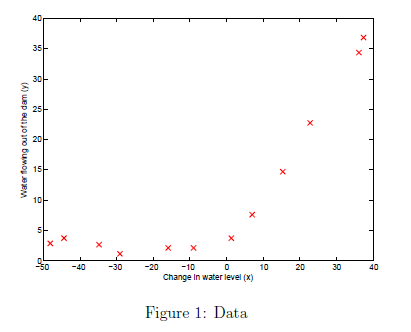

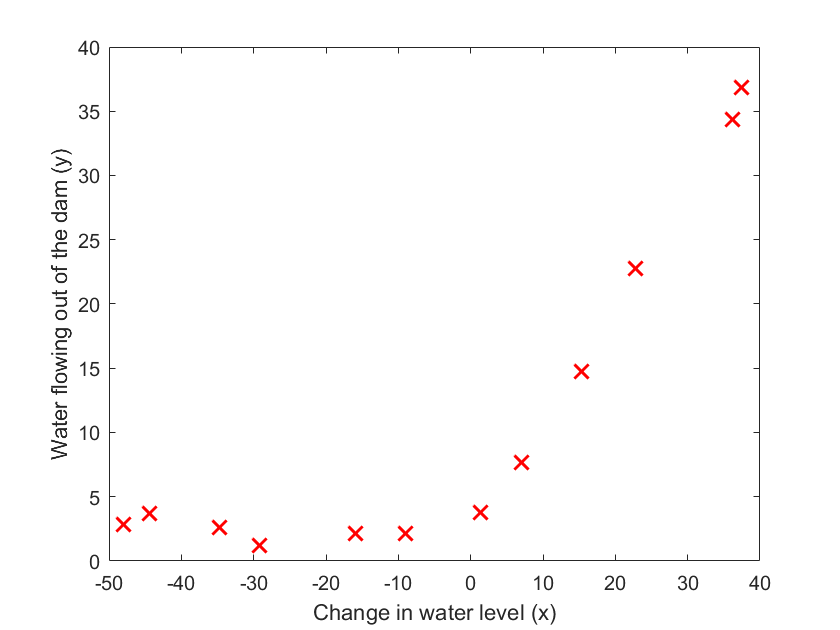

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment

load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

Cost at theta = [1 ; 1]: 303.993192

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j>0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01
Iteration     4 | Cost: 2.237391e+01
Iteration     5 | Cost: 2.237391e+01


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

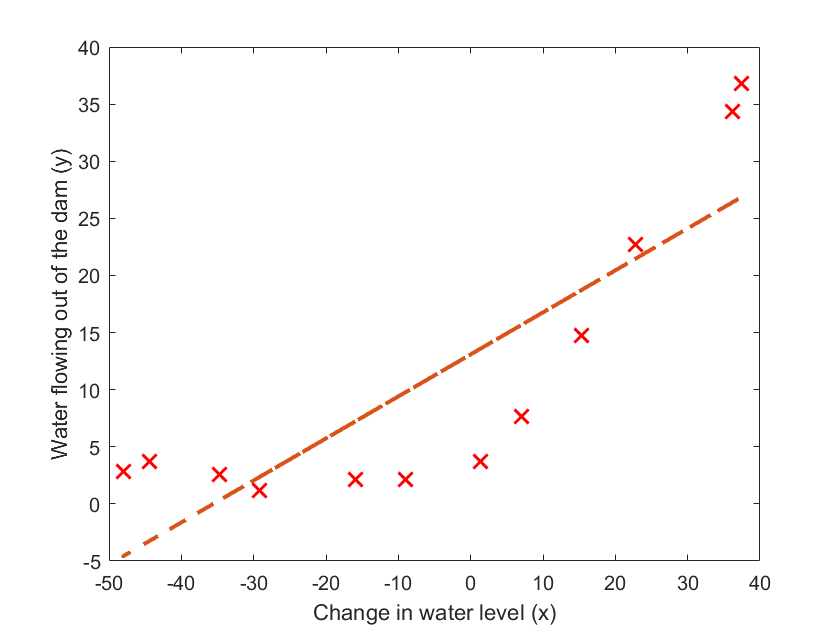

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     3 | Cost: 3.286595e+00
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.842916e+00
Iteration     7 | Cost: 2.842916e+00
Iteration     8 | Cost: 2.842770e+00
Iteration     9 | Cost: 2.842731e+00
Iteration    10 | Cost: 2.842729e+00
Iteration    11 | Cost: 2.842678e+00
Iteration     1 | Cost: 1.592641e+02
Iteration     2 | Cost: 2.404966e+01
Iteration     3 | Cost: 2.354137e+01
Iteration     4 | Cost: 2.281160e+01
Iteration     5 | Cost: 2.276969e+01
Iteration     6 | Cost: 2.224060e+01
Iteration     7 | Cost: 1.920606e+01
I

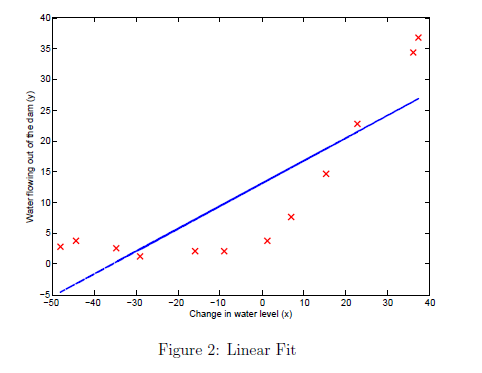

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

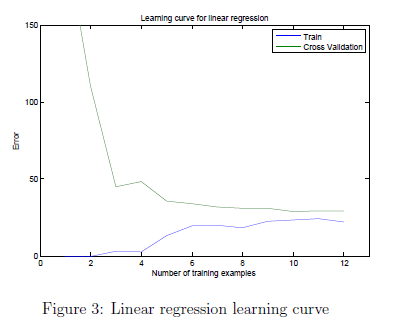

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

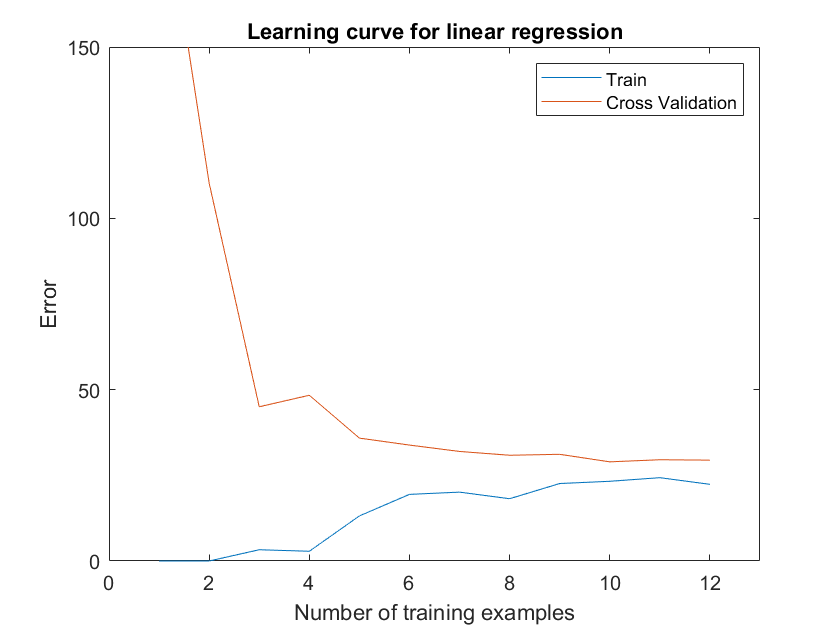

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')

xlabel('Number of training examples')
ylabel('Error')

# Training Examples	Train Error	Cross Validation Error


axis([0 13 0 150])

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.412590e-01
Iteration    11 | Cost: 7.550869e-01
Iteration    12 | Cost: 6.855320e-01
Iteration    13 | Cost: 6.178329e-01
Iteration    14 | Cost: 5.205509e-01
Iteration    15 | Cost: 5.114803e-01
Iteration    16 | Cost: 4.748578e-01
Iteration    17 | Cost: 4.511986e-01
Iteration    18 | Cost: 4.350876e-01
Iteration    19 | Cost: 4.181775e-01
Iteration    20 | Cost: 4.112587e-01
Iteration    21 | Cost: 4.098682e-01
Iteration    22 | Cost: 3.584294e-01
Iteration    23 | Cost: 3.504672e-01
Iteration    24 | Cost: 3.412308e-01
Iteration    25 | Cost: 3.374517e-01
Iteration    26 | Cost: 3.337411e-01
Iteration    27 | Cost: 3.299746e-01
I

    After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

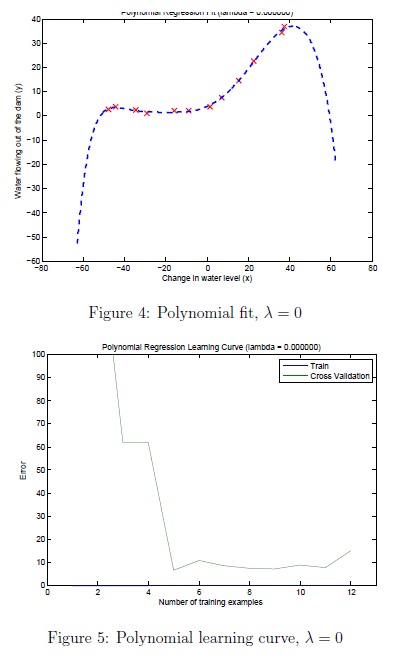

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

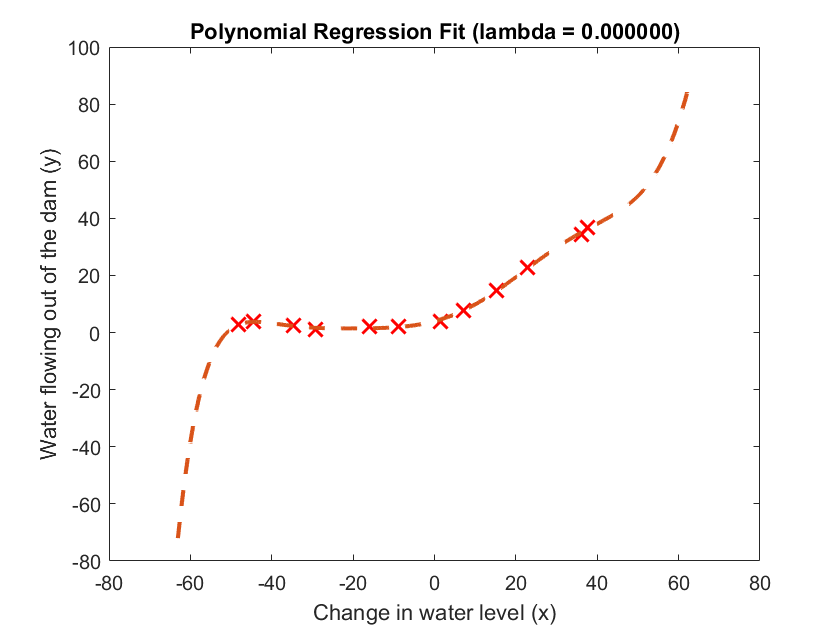

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

plot(1:m, error_train, 1:m, error_val);

Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 9.860761e-32
Iteration     4 | Cost: 0.000000e+00
Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 4.560072e-11
Iteration     5 | Cost: 4.560059e-11
Iteration     6 | Cost: 2.309960e-11
Iteration     7 | Cost: 1.551252e-14
Iteration     8 | Cost: 1.550239e-14
Iteration     9 | Cost: 7.917902e-15
Iteration    10 | Cost: 5.482829e-17
Iteration    11 | Cost: 3.321856e-17
Iteration    12 | Cost: 4.062935e-18
Iteration    13 | Cost: 3.711338e-18
Iteration    14 | Cost: 9.611423e-19
Iteration    15 | Cost: 5.369185e-29
Iteration    16 | Cost: 1.232595e-32
Iteration    17 | Cost: 0.000000e+00
Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
I

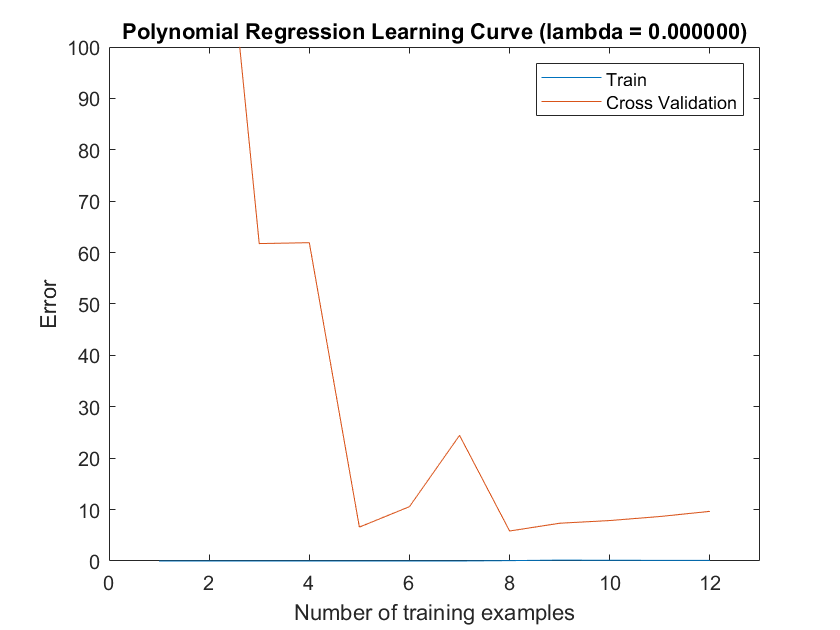

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit

Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 9.152504e+00
Iteration     5 | Cost: 8.191432e+00
Iteration     6 | Cost: 7.658009e+00
Iteration     7 | Cost: 7.558221e+00
Iteration     8 | Cost: 7.492673e+00
Iteration     9 | Cost: 7.447063e+00
Iteration    10 | Cost: 7.373583e+00
Iteration    11 | Cost: 7.324290e+00
Iteration    12 | Cost: 7.294683e+00
Iteration    13 | Cost: 7.277011e+00
Iteration    14 | Cost: 7.270400e+00
Iteration    15 | Cost: 7.269354e+00
Iteration    16 | Cost: 7.269082e+00
Iteration    17 | Cost: 7.268182e+00
Iteration    18 | Cost: 7.268179e+00
Iteration    19 | Cost: 7.268171e+00
Iteration    20 | Cost: 7.268167e+00
Iteration    21 | Cost: 7.268155e+00
Iteration    22 | Cost: 7.268154e+00
Iteration    23 | Cost: 7.268152e+00
Iteration    24 | Cost: 7.268151e+00
Iteration    25 | Cost: 7.268150e+00
Iteration    26 | Cost: 7.268150e+00
Iteration    27 | Cost: 7.268149e+00
I

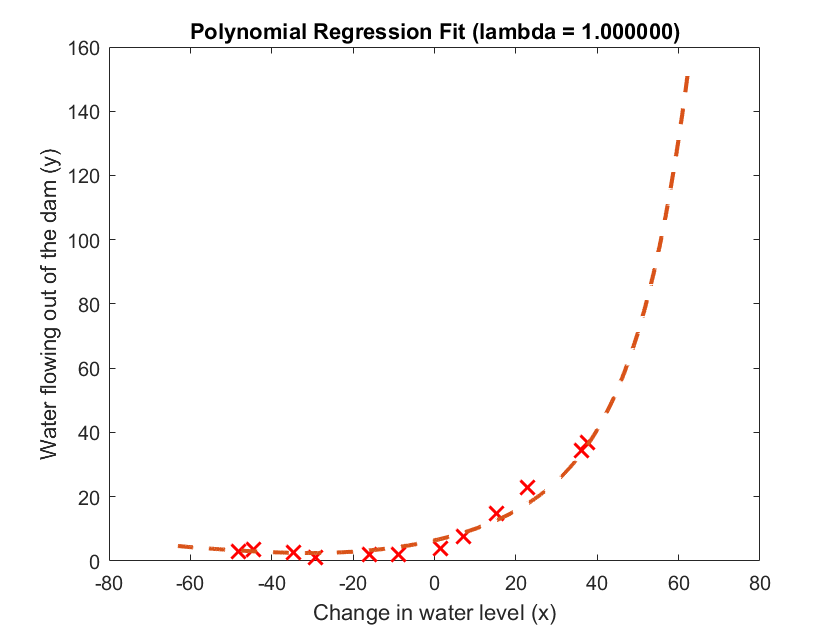

plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));

Iteration     1 | Cost: 5.280051e-01
Iteration     2 | Cost: 2.083531e-01
Iteration     3 | Cost: 9.810873e-02
Iteration     4 | Cost: 1.501116e-03
Iteration     5 | Cost: 1.089480e-03
Iteration     6 | Cost: 4.451497e-31
Iteration     7 | Cost: 3.829364e-31
Iteration     8 | Cost: 1.258474e-31
Iteration     9 | Cost: 1.098718e-31
Iteration     1 | Cost: 2.032751e-01
Iteration     2 | Cost: 1.041953e-01
Iteration     3 | Cost: 7.367762e-02
Iteration     4 | Cost: 7.279642e-02
Iteration     5 | Cost: 7.269797e-02
Iteration     6 | Cost: 7.269533e-02
Iteration     7 | Cost: 7.269502e-02
Iteration     8 | Cost: 7.269437e-02
Iteration     9 | Cost: 7.269436e-02
Iteration    10 | Cost: 7.269436e-02
Iteration    11 | Cost: 7.269436e-02
Iteration    12 | Cost: 7.269436e-02
Iteration    13 | Cost: 7.269436e-02
Iteration    14 | Cost: 7.269436e-02
Iteration    15 | Cost: 7.269436e-02
Iteration    16 | Cost: 7.269436e-02
Iteration    17 | Cost: 7.269436e-02
Iteration    18 | Cost: 7.269436e-02
I

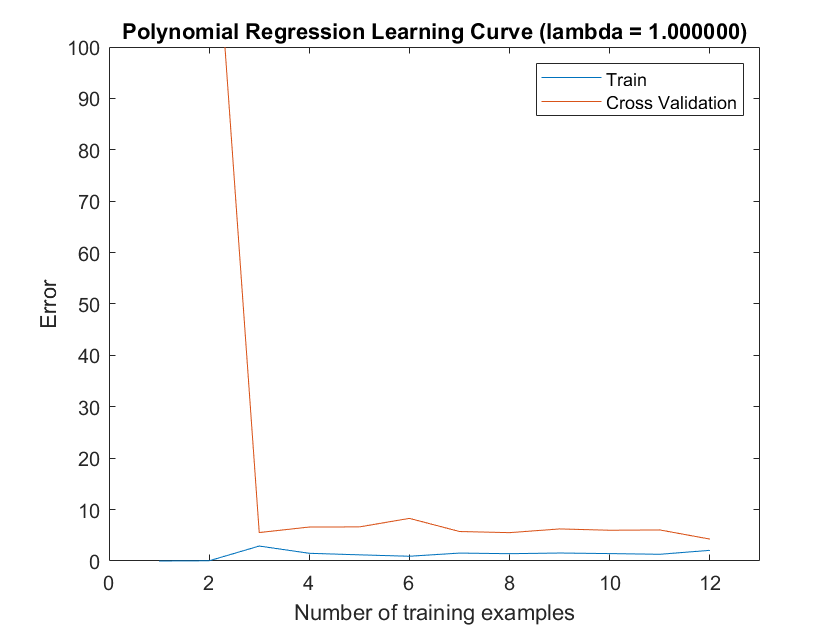

xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

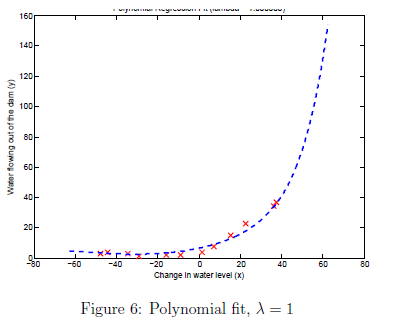

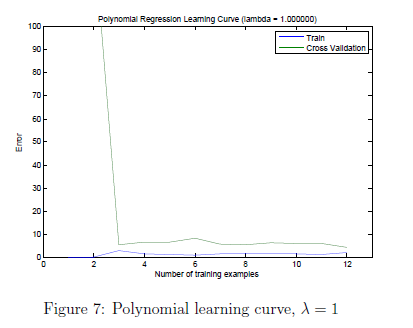

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

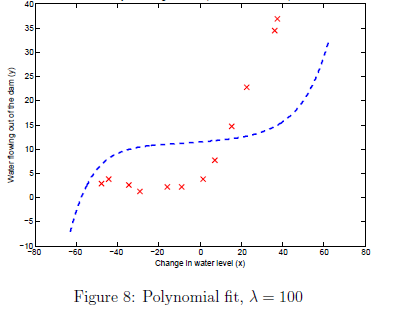

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.412590e-01
Iteration    11 | Cost: 7.550869e-01
Iteration    12 | Cost: 6.855320e-01
Iteration    13 | Cost: 6.178329e-01
Iteration    14 | Cost: 5.205509e-01
Iteration    15 | Cost: 5.114803e-01
Iteration    16 | Cost: 4.748578e-01
Iteration    17 | Cost: 4.511986e-01
Iteration    18 | Cost: 4.350876e-01
Iteration    19 | Cost: 4.181775e-01
Iteration    20 | Cost: 4.112587e-01
Iteration    21 | Cost: 4.098682e-01
Iteration    22 | Cost: 3.584294e-01
Iteration    23 | Cost: 3.504672e-01
Iteration    24 | Cost: 3.412308e-01
Iteration    25 | Cost: 3.374517e-01
Iteration    26 | Cost: 3.337411e-01
Iteration    27 | Cost: 3.299746e-01
I

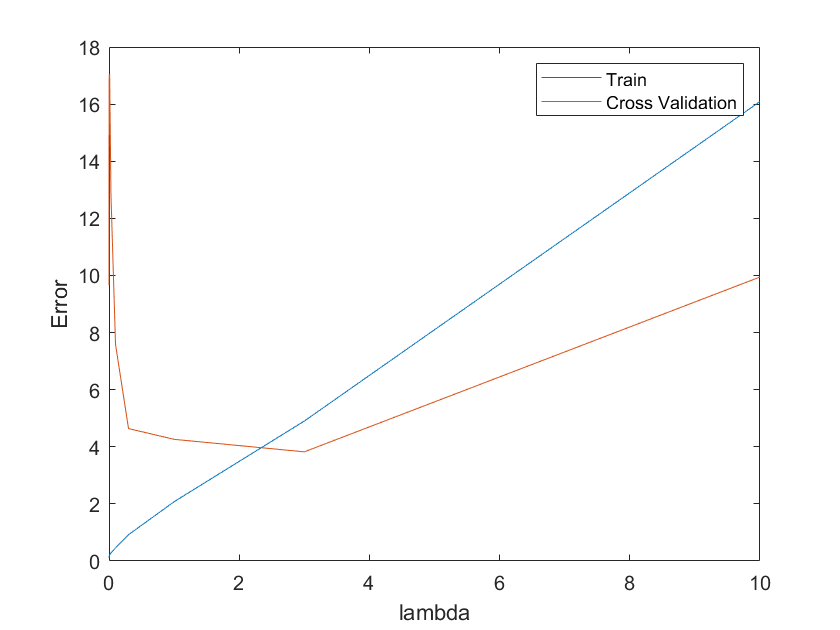

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end

    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.110973	9.660705
0.001000	0.148236	15.230900
0.003000	0.176307	16.997118
0.010000	0.222267	17.042475
0.030000	0.281892	12.833116
0.100000	0.459318	7.587014
0.300000	0.921760	4.636833
1.000000	2.076188	4.260625
3.000000	4.901351	3.822907
10.000000	16.092213	9.945509


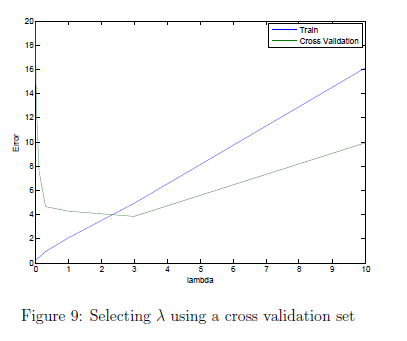

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%
lambda = 3; 
theta = trainLinearReg(X_poly,y,lambda);
test_error = linearRegCostFunction(X_poly_test,ytest,theta,0)


### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;

Iteration     1 | Cost: 8.416707e+01
Iteration     2 | Cost: 3.345965e+01
Iteration     3 | Cost: 2.112694e+01
Iteration     4 | Cost: 1.621542e+01
Iteration     5 | Cost: 1.605198e+01
Iteration     6 | Cost: 1.596514e+01
Iteration     7 | Cost: 1.596285e+01
Iteration     8 | Cost: 1.592089e+01
Iteration     9 | Cost: 1.589157e+01
Iteration    10 | Cost: 1.589011e+01
Iteration    11 | Cost: 1.587849e+01
Iteration    12 | Cost: 1.587363e+01
Iteration    13 | Cost: 1.586793e+01
Iteration    14 | Cost: 1.586791e+01
Iteration    15 | Cost: 1.586776e+01
Iteration    16 | Cost: 1.586772e+01
Iteration    17 | Cost: 1.586769e+01
Iteration    18 | Cost: 1.586769e+01
Iteration    19 | Cost: 1.586769e+01
Iteration    20 | Cost: 1.586769e+01
Iteration    21 | Cost: 1.586769e+01
Iteration    22 | Cost: 1.586769e+01
Iteration    23 | Cost: 1.586769e+01
Iteration    24 | Cost: 1.586769e+01
Iteration    25 | Cost: 1.586769e+01
Iteration    26 | Cost: 1.586769e+01
Iteration    27 | Cost: 1.586769e+01
I

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

test_error = 3.8599

Iteration     1 | Cost: 5.772715e-02
Iteration     2 | Cost: 6.209542e-03
Iteration     3 | Cost: 1.126979e-04
Iteration     4 | Cost: 9.320684e-07
Iteration     5 | Cost: 3.203397e-08
Iteration     6 | Cost: 3.202999e-08
Iteration     7 | Cost: 3.187490e-08
Iteration     8 | Cost: 2.820343e-08
Iteration     9 | Cost: 4.423386e-09
Iteration    10 | Cost: 1.328966e-13
Iteration    11 | Cost: 7.871594e-15
Iteration    12 | Cost: 7.768562e-15
Iteration    13 | Cost: 1.824170e-27
Iteration    14 | Cost: 1.197502e-28
Iteration    15 | Cost: 4.073079e-30
Iteration    16 | Cost: 3.765215e-30


Jval = 94.7594

Iteration     1 | Cost: 5.282417e-01
Iteration     2 | Cost: 3.661465e-02
Iteration     3 | Cost: 1.365125e-03
Iteration     4 | Cost: 1.877010e-04
Iteration     5 | Cost: 2.376015e-05
Iteration     6 | Cost: 1.581967e-28
Iteration     7 | Cost: 6.506972e-30
Iteration     8 | Cost: 4.339857e-31
Iteration    10 | Cost: 3.774313e-31


Jval =    94.7594  129.2962


Iteration     1 | Cost: 9.576900e-01
Iteration     2 | Cost: 1.382735e-02
Iteration     3 | Cost: 2.267200e-03
Iteration     4 | Cost: 2.013327e-03
Iteration     5 | Cost: 1.854432e-03
Iteration     6 | Cost: 9.731807e-05
Iteration     7 | Cost: 9.654430e-05
Iteration     8 | Cost: 8.642515e-05
Iteration     9 | Cost: 8.639931e-05
Iteration    10 | Cost: 8.563448e-05
Iteration    11 | Cost: 3.630193e-05
Iteration    12 | Cost: 4.990597e-06
Iteration    13 | Cost: 3.390322e-06
Iteration    14 | Cost: 3.658232e-07
Iteration    15 | Cost: 3.495258e-07
Iteration    16 | Cost: 2.865238e-07
Iteration    17 | Cost: 7.533309e-08
Iteration    18 | Cost: 6.313722e-09
Iteration    19 | Cost: 5.591001e-10
Iteration    20 | Cost: 1.352595e-10
Iteration    21 | Cost: 5.302603e-11
Iteration    22 | Cost: 3.578866e-19
Iteration    23 | Cost: 1.391293e-20
Iteration    24 | Cost: 3.464102e-21
Iteration    25 | Cost: 1.058973e-29
Iteration    26 | Cost: 2.940687e-30
Iteration    27 | Cost: 2.212696e-30
I

Jval =    94.7594  129.2962  122.8374


Iteration     1 | Cost: 8.861557e-01
Iteration     2 | Cost: 3.858909e-03
Iteration     3 | Cost: 1.919122e-04
Iteration     4 | Cost: 1.620714e-04
Iteration     5 | Cost: 1.475633e-04
Iteration     6 | Cost: 1.360899e-05
Iteration     7 | Cost: 1.434570e-07
Iteration     8 | Cost: 1.127399e-09
Iteration     9 | Cost: 7.766098e-11
Iteration    10 | Cost: 2.352633e-11
Iteration    11 | Cost: 5.795300e-13
Iteration    12 | Cost: 5.484443e-13
Iteration    13 | Cost: 5.101044e-13
Iteration    14 | Cost: 5.097700e-13
Iteration    15 | Cost: 4.610901e-25
Iteration    16 | Cost: 2.017146e-26
Iteration    17 | Cost: 4.455667e-27
Iteration    18 | Cost: 5.264164e-29
Iteration    19 | Cost: 1.075626e-31


Jval =    94.7594  129.2962  122.8374  122.9152


Iteration     1 | Cost: 9.576900e-01
Iteration     2 | Cost: 1.382735e-02
Iteration     3 | Cost: 2.267200e-03
Iteration     4 | Cost: 2.013327e-03
Iteration     5 | Cost: 1.854432e-03
Iteration     6 | Cost: 9.731807e-05
Iteration     7 | Cost: 9.654430e-05
Iteration     8 | Cost: 8.642515e-05
Iteration     9 | Cost: 8.639931e-05
Iteration    10 | Cost: 8.563448e-05
Iteration    11 | Cost: 3.630193e-05
Iteration    12 | Cost: 4.990597e-06
Iteration    13 | Cost: 3.390322e-06
Iteration    14 | Cost: 3.658232e-07
Iteration    15 | Cost: 3.495258e-07
Iteration    16 | Cost: 2.865238e-07
Iteration    17 | Cost: 7.533309e-08
Iteration    18 | Cost: 6.313722e-09
Iteration    19 | Cost: 5.591001e-10
Iteration    20 | Cost: 1.352595e-10
Iteration    21 | Cost: 5.302603e-11
Iteration    22 | Cost: 3.578866e-19
Iteration    23 | Cost: 1.391293e-20
Iteration    24 | Cost: 3.464102e-21
Iteration    25 | Cost: 1.058973e-29
Iteration    26 | Cost: 2.940687e-30
Iteration    27 | Cost: 2.212696e-30
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374


Iteration     1 | Cost: 8.895239e-04
Iteration     2 | Cost: 6.000734e-28
Iteration     3 | Cost: 1.531269e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068


Iteration     1 | Cost: 7.959924e-03
Iteration     2 | Cost: 2.982931e-28
Iteration     3 | Cost: 9.830261e-31
Iteration     4 | Cost: 5.851920e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926


Iteration     1 | Cost: 8.668914e+01
Iteration     2 | Cost: 7.745617e-01
Iteration     3 | Cost: 1.464056e-01
Iteration     4 | Cost: 1.392526e-01
Iteration     5 | Cost: 1.351535e-01
Iteration     6 | Cost: 4.201282e-03
Iteration     7 | Cost: 3.732281e-03
Iteration     8 | Cost: 3.080270e-03
Iteration     9 | Cost: 2.448806e-03
Iteration    10 | Cost: 5.781147e-04
Iteration    11 | Cost: 1.827144e-04
Iteration    12 | Cost: 8.543821e-05
Iteration    13 | Cost: 1.640227e-06
Iteration    14 | Cost: 3.484646e-07
Iteration    15 | Cost: 4.186501e-08
Iteration    16 | Cost: 2.896500e-08
Iteration    17 | Cost: 1.441175e-08
Iteration    18 | Cost: 7.389925e-09
Iteration    19 | Cost: 3.666049e-10
Iteration    20 | Cost: 4.406047e-11
Iteration    21 | Cost: 2.826073e-11
Iteration    22 | Cost: 1.223185e-11
Iteration    23 | Cost: 1.184768e-12
Iteration    24 | Cost: 1.156086e-12
Iteration    25 | Cost: 8.657855e-13
Iteration    26 | Cost: 5.082333e-13
Iteration    27 | Cost: 1.252219e-13
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313


Iteration     1 | Cost: 9.576900e-01
Iteration     2 | Cost: 1.382735e-02
Iteration     3 | Cost: 2.267200e-03
Iteration     4 | Cost: 2.013327e-03
Iteration     5 | Cost: 1.854432e-03
Iteration     6 | Cost: 9.731807e-05
Iteration     7 | Cost: 9.654430e-05
Iteration     8 | Cost: 8.642515e-05
Iteration     9 | Cost: 8.639931e-05
Iteration    10 | Cost: 8.563448e-05
Iteration    11 | Cost: 3.630193e-05
Iteration    12 | Cost: 4.990597e-06
Iteration    13 | Cost: 3.390322e-06
Iteration    14 | Cost: 3.658232e-07
Iteration    15 | Cost: 3.495258e-07
Iteration    16 | Cost: 2.865238e-07
Iteration    17 | Cost: 7.533309e-08
Iteration    18 | Cost: 6.313722e-09
Iteration    19 | Cost: 5.591001e-10
Iteration    20 | Cost: 1.352595e-10
Iteration    21 | Cost: 5.302603e-11
Iteration    22 | Cost: 3.578866e-19
Iteration    23 | Cost: 1.391293e-20
Iteration    24 | Cost: 3.464102e-21
Iteration    25 | Cost: 1.058973e-29
Iteration    26 | Cost: 2.940687e-30
Iteration    27 | Cost: 2.212696e-30
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374


Iteration     1 | Cost: 3.405390e-01
Iteration     2 | Cost: 4.988078e-03
Iteration     3 | Cost: 2.151804e-04
Iteration     4 | Cost: 1.111526e-04
Iteration     5 | Cost: 5.971823e-05
Iteration     6 | Cost: 1.149113e-06
Iteration     7 | Cost: 1.118191e-06
Iteration     8 | Cost: 5.589559e-07
Iteration     9 | Cost: 2.324464e-08
Iteration    10 | Cost: 2.323681e-08
Iteration    11 | Cost: 2.302666e-08
Iteration    12 | Cost: 1.565767e-09
Iteration    13 | Cost: 1.565301e-09
Iteration    14 | Cost: 1.550797e-09
Iteration    15 | Cost: 1.155014e-09
Iteration    16 | Cost: 3.935449e-11
Iteration    17 | Cost: 7.973210e-12
Iteration    18 | Cost: 3.407584e-12
Iteration    19 | Cost: 3.935525e-13
Iteration    20 | Cost: 1.649361e-14
Iteration    21 | Cost: 4.690652e-15
Iteration    22 | Cost: 6.854626e-18
Iteration    23 | Cost: 6.829517e-18
Iteration    24 | Cost: 6.793342e-18
Iteration    25 | Cost: 6.629255e-18
Iteration    26 | Cost: 4.750809e-18
Iteration    27 | Cost: 2.573025e-18
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468


Iteration     1 | Cost: 1.455857e+02
Iteration     2 | Cost: 7.804426e-01
Iteration     3 | Cost: 3.201977e-03
Iteration     4 | Cost: 3.140316e-28


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811


Iteration     1 | Cost: 3.405390e-01
Iteration     2 | Cost: 4.988078e-03
Iteration     3 | Cost: 2.151804e-04
Iteration     4 | Cost: 1.111526e-04
Iteration     5 | Cost: 5.971823e-05
Iteration     6 | Cost: 1.149113e-06
Iteration     7 | Cost: 1.118191e-06
Iteration     8 | Cost: 5.589559e-07
Iteration     9 | Cost: 2.324464e-08
Iteration    10 | Cost: 2.323681e-08
Iteration    11 | Cost: 2.302666e-08
Iteration    12 | Cost: 1.565767e-09
Iteration    13 | Cost: 1.565301e-09
Iteration    14 | Cost: 1.550797e-09
Iteration    15 | Cost: 1.155014e-09
Iteration    16 | Cost: 3.935449e-11
Iteration    17 | Cost: 7.973210e-12
Iteration    18 | Cost: 3.407584e-12
Iteration    19 | Cost: 3.935525e-13
Iteration    20 | Cost: 1.649361e-14
Iteration    21 | Cost: 4.690652e-15
Iteration    22 | Cost: 6.854626e-18
Iteration    23 | Cost: 6.829517e-18
Iteration    24 | Cost: 6.793342e-18
Iteration    25 | Cost: 6.629255e-18
Iteration    26 | Cost: 4.750809e-18
Iteration    27 | Cost: 2.573025e-18
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468


Iteration     1 | Cost: 1.393524e-01
Iteration     2 | Cost: 1.682736e-03
Iteration     3 | Cost: 1.757164e-05
Iteration     4 | Cost: 2.529527e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613


Iteration     1 | Cost: 8.861557e-01
Iteration     2 | Cost: 3.858909e-03
Iteration     3 | Cost: 1.919122e-04
Iteration     4 | Cost: 1.620714e-04
Iteration     5 | Cost: 1.475633e-04
Iteration     6 | Cost: 1.360899e-05
Iteration     7 | Cost: 1.434570e-07
Iteration     8 | Cost: 1.127399e-09
Iteration     9 | Cost: 7.766098e-11
Iteration    10 | Cost: 2.352633e-11
Iteration    11 | Cost: 5.795300e-13
Iteration    12 | Cost: 5.484443e-13
Iteration    13 | Cost: 5.101044e-13
Iteration    14 | Cost: 5.097700e-13
Iteration    15 | Cost: 4.610901e-25
Iteration    16 | Cost: 2.017146e-26
Iteration    17 | Cost: 4.455667e-27
Iteration    18 | Cost: 5.264164e-29
Iteration    19 | Cost: 1.075626e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152


Iteration     1 | Cost: 9.576900e-01
Iteration     2 | Cost: 1.382735e-02
Iteration     3 | Cost: 2.267200e-03
Iteration     4 | Cost: 2.013327e-03
Iteration     5 | Cost: 1.854432e-03
Iteration     6 | Cost: 9.731807e-05
Iteration     7 | Cost: 9.654430e-05
Iteration     8 | Cost: 8.642515e-05
Iteration     9 | Cost: 8.639931e-05
Iteration    10 | Cost: 8.563448e-05
Iteration    11 | Cost: 3.630193e-05
Iteration    12 | Cost: 4.990597e-06
Iteration    13 | Cost: 3.390322e-06
Iteration    14 | Cost: 3.658232e-07
Iteration    15 | Cost: 3.495258e-07
Iteration    16 | Cost: 2.865238e-07
Iteration    17 | Cost: 7.533309e-08
Iteration    18 | Cost: 6.313722e-09
Iteration    19 | Cost: 5.591001e-10
Iteration    20 | Cost: 1.352595e-10
Iteration    21 | Cost: 5.302603e-11
Iteration    22 | Cost: 3.578866e-19
Iteration    23 | Cost: 1.391293e-20
Iteration    24 | Cost: 3.464102e-21
Iteration    25 | Cost: 1.058973e-29
Iteration    26 | Cost: 2.940687e-30
Iteration    27 | Cost: 2.212696e-30
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374


Iteration     1 | Cost: 1.455857e+02
Iteration     2 | Cost: 7.804426e-01
Iteration     3 | Cost: 3.201977e-03
Iteration     4 | Cost: 3.140316e-28


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811


Iteration     1 | Cost: 5.282417e-01
Iteration     2 | Cost: 3.661465e-02
Iteration     3 | Cost: 1.365125e-03
Iteration     4 | Cost: 1.877010e-04
Iteration     5 | Cost: 2.376015e-05
Iteration     6 | Cost: 1.581967e-28
Iteration     7 | Cost: 6.506972e-30
Iteration     8 | Cost: 4.339857e-31
Iteration    10 | Cost: 3.774313e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962


Iteration     1 | Cost: 3.405390e-01
Iteration     2 | Cost: 4.988078e-03
Iteration     3 | Cost: 2.151804e-04
Iteration     4 | Cost: 1.111526e-04
Iteration     5 | Cost: 5.971823e-05
Iteration     6 | Cost: 1.149113e-06
Iteration     7 | Cost: 1.118191e-06
Iteration     8 | Cost: 5.589559e-07
Iteration     9 | Cost: 2.324464e-08
Iteration    10 | Cost: 2.323681e-08
Iteration    11 | Cost: 2.302666e-08
Iteration    12 | Cost: 1.565767e-09
Iteration    13 | Cost: 1.565301e-09
Iteration    14 | Cost: 1.550797e-09
Iteration    15 | Cost: 1.155014e-09
Iteration    16 | Cost: 3.935449e-11
Iteration    17 | Cost: 7.973210e-12
Iteration    18 | Cost: 3.407584e-12
Iteration    19 | Cost: 3.935525e-13
Iteration    20 | Cost: 1.649361e-14
Iteration    21 | Cost: 4.690652e-15
Iteration    22 | Cost: 6.854626e-18
Iteration    23 | Cost: 6.829517e-18
Iteration    24 | Cost: 6.793342e-18
Iteration    25 | Cost: 6.629255e-18
Iteration    26 | Cost: 4.750809e-18
Iteration    27 | Cost: 2.573025e-18
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468


Iteration     1 | Cost: 3.163983e-01
Iteration     2 | Cost: 4.637162e-03
Iteration     3 | Cost: 5.044500e-04
Iteration     4 | Cost: 4.108489e-04
Iteration     5 | Cost: 3.511045e-04
Iteration     6 | Cost: 8.432286e-05
Iteration     7 | Cost: 7.876056e-05
Iteration     8 | Cost: 6.396240e-05
Iteration     9 | Cost: 5.986374e-06
Iteration    10 | Cost: 5.960258e-06
Iteration    11 | Cost: 5.697865e-06
Iteration    12 | Cost: 3.725202e-06
Iteration    13 | Cost: 1.110073e-06
Iteration    14 | Cost: 2.773625e-07
Iteration    15 | Cost: 7.866013e-08
Iteration    16 | Cost: 3.734717e-08
Iteration    17 | Cost: 2.109576e-08
Iteration    18 | Cost: 1.112433e-09
Iteration    19 | Cost: 9.483591e-10
Iteration    20 | Cost: 4.581906e-10
Iteration    21 | Cost: 2.231795e-12
Iteration    22 | Cost: 2.190128e-12
Iteration    23 | Cost: 5.179788e-13
Iteration    24 | Cost: 5.156586e-13
Iteration    25 | Cost: 5.062708e-13
Iteration    26 | Cost: 4.780273e-13
Iteration    27 | Cost: 1.610543e-15
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895


Iteration     1 | Cost: 8.895239e-04
Iteration     2 | Cost: 6.000734e-28
Iteration     3 | Cost: 1.531269e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068


Iteration     1 | Cost: 8.861557e-01
Iteration     2 | Cost: 3.858909e-03
Iteration     3 | Cost: 1.919122e-04
Iteration     4 | Cost: 1.620714e-04
Iteration     5 | Cost: 1.475633e-04
Iteration     6 | Cost: 1.360899e-05
Iteration     7 | Cost: 1.434570e-07
Iteration     8 | Cost: 1.127399e-09
Iteration     9 | Cost: 7.766098e-11
Iteration    10 | Cost: 2.352633e-11
Iteration    11 | Cost: 5.795300e-13
Iteration    12 | Cost: 5.484443e-13
Iteration    13 | Cost: 5.101044e-13
Iteration    14 | Cost: 5.097700e-13
Iteration    15 | Cost: 4.610901e-25
Iteration    16 | Cost: 2.017146e-26
Iteration    17 | Cost: 4.455667e-27
Iteration    18 | Cost: 5.264164e-29
Iteration    19 | Cost: 1.075626e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152


Iteration     1 | Cost: 8.861557e-01
Iteration     2 | Cost: 3.858909e-03
Iteration     3 | Cost: 1.919122e-04
Iteration     4 | Cost: 1.620714e-04
Iteration     5 | Cost: 1.475633e-04
Iteration     6 | Cost: 1.360899e-05
Iteration     7 | Cost: 1.434570e-07
Iteration     8 | Cost: 1.127399e-09
Iteration     9 | Cost: 7.766098e-11
Iteration    10 | Cost: 2.352633e-11
Iteration    11 | Cost: 5.795300e-13
Iteration    12 | Cost: 5.484443e-13
Iteration    13 | Cost: 5.101044e-13
Iteration    14 | Cost: 5.097700e-13
Iteration    15 | Cost: 4.610901e-25
Iteration    16 | Cost: 2.017146e-26
Iteration    17 | Cost: 4.455667e-27
Iteration    18 | Cost: 5.264164e-29
Iteration    19 | Cost: 1.075626e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152


Iteration     1 | Cost: 8.668914e+01
Iteration     2 | Cost: 7.745617e-01
Iteration     3 | Cost: 1.464056e-01
Iteration     4 | Cost: 1.392526e-01
Iteration     5 | Cost: 1.351535e-01
Iteration     6 | Cost: 4.201282e-03
Iteration     7 | Cost: 3.732281e-03
Iteration     8 | Cost: 3.080270e-03
Iteration     9 | Cost: 2.448806e-03
Iteration    10 | Cost: 5.781147e-04
Iteration    11 | Cost: 1.827144e-04
Iteration    12 | Cost: 8.543821e-05
Iteration    13 | Cost: 1.640227e-06
Iteration    14 | Cost: 3.484646e-07
Iteration    15 | Cost: 4.186501e-08
Iteration    16 | Cost: 2.896500e-08
Iteration    17 | Cost: 1.441175e-08
Iteration    18 | Cost: 7.389925e-09
Iteration    19 | Cost: 3.666049e-10
Iteration    20 | Cost: 4.406047e-11
Iteration    21 | Cost: 2.826073e-11
Iteration    22 | Cost: 1.223185e-11
Iteration    23 | Cost: 1.184768e-12
Iteration    24 | Cost: 1.156086e-12
Iteration    25 | Cost: 8.657855e-13
Iteration    26 | Cost: 5.082333e-13
Iteration    27 | Cost: 1.252219e-13
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313


Iteration     1 | Cost: 3.163983e-01
Iteration     2 | Cost: 4.637162e-03
Iteration     3 | Cost: 5.044500e-04
Iteration     4 | Cost: 4.108489e-04
Iteration     5 | Cost: 3.511045e-04
Iteration     6 | Cost: 8.432286e-05
Iteration     7 | Cost: 7.876056e-05
Iteration     8 | Cost: 6.396240e-05
Iteration     9 | Cost: 5.986374e-06
Iteration    10 | Cost: 5.960258e-06
Iteration    11 | Cost: 5.697865e-06
Iteration    12 | Cost: 3.725202e-06
Iteration    13 | Cost: 1.110073e-06
Iteration    14 | Cost: 2.773625e-07
Iteration    15 | Cost: 7.866013e-08
Iteration    16 | Cost: 3.734717e-08
Iteration    17 | Cost: 2.109576e-08
Iteration    18 | Cost: 1.112433e-09
Iteration    19 | Cost: 9.483591e-10
Iteration    20 | Cost: 4.581906e-10
Iteration    21 | Cost: 2.231795e-12
Iteration    22 | Cost: 2.190128e-12
Iteration    23 | Cost: 5.179788e-13
Iteration    24 | Cost: 5.156586e-13
Iteration    25 | Cost: 5.062708e-13
Iteration    26 | Cost: 4.780273e-13
Iteration    27 | Cost: 1.610543e-15
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895


Iteration     1 | Cost: 3.163983e-01
Iteration     2 | Cost: 4.637162e-03
Iteration     3 | Cost: 5.044500e-04
Iteration     4 | Cost: 4.108489e-04
Iteration     5 | Cost: 3.511045e-04
Iteration     6 | Cost: 8.432286e-05
Iteration     7 | Cost: 7.876056e-05
Iteration     8 | Cost: 6.396240e-05
Iteration     9 | Cost: 5.986374e-06
Iteration    10 | Cost: 5.960258e-06
Iteration    11 | Cost: 5.697865e-06
Iteration    12 | Cost: 3.725202e-06
Iteration    13 | Cost: 1.110073e-06
Iteration    14 | Cost: 2.773625e-07
Iteration    15 | Cost: 7.866013e-08
Iteration    16 | Cost: 3.734717e-08
Iteration    17 | Cost: 2.109576e-08
Iteration    18 | Cost: 1.112433e-09
Iteration    19 | Cost: 9.483591e-10
Iteration    20 | Cost: 4.581906e-10
Iteration    21 | Cost: 2.231795e-12
Iteration    22 | Cost: 2.190128e-12
Iteration    23 | Cost: 5.179788e-13
Iteration    24 | Cost: 5.156586e-13
Iteration    25 | Cost: 5.062708e-13
Iteration    26 | Cost: 4.780273e-13
Iteration    27 | Cost: 1.610543e-15
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895


Iteration     1 | Cost: 7.959924e-03
Iteration     2 | Cost: 2.982931e-28
Iteration     3 | Cost: 9.830261e-31
Iteration     4 | Cost: 5.851920e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926


Iteration     1 | Cost: 9.576900e-01
Iteration     2 | Cost: 1.382735e-02
Iteration     3 | Cost: 2.267200e-03
Iteration     4 | Cost: 2.013327e-03
Iteration     5 | Cost: 1.854432e-03
Iteration     6 | Cost: 9.731807e-05
Iteration     7 | Cost: 9.654430e-05
Iteration     8 | Cost: 8.642515e-05
Iteration     9 | Cost: 8.639931e-05
Iteration    10 | Cost: 8.563448e-05
Iteration    11 | Cost: 3.630193e-05
Iteration    12 | Cost: 4.990597e-06
Iteration    13 | Cost: 3.390322e-06
Iteration    14 | Cost: 3.658232e-07
Iteration    15 | Cost: 3.495258e-07
Iteration    16 | Cost: 2.865238e-07
Iteration    17 | Cost: 7.533309e-08
Iteration    18 | Cost: 6.313722e-09
Iteration    19 | Cost: 5.591001e-10
Iteration    20 | Cost: 1.352595e-10
Iteration    21 | Cost: 5.302603e-11
Iteration    22 | Cost: 3.578866e-19
Iteration    23 | Cost: 1.391293e-20
Iteration    24 | Cost: 3.464102e-21
Iteration    25 | Cost: 1.058973e-29
Iteration    26 | Cost: 2.940687e-30
Iteration    27 | Cost: 2.212696e-30
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374


Iteration     1 | Cost: 8.861557e-01
Iteration     2 | Cost: 3.858909e-03
Iteration     3 | Cost: 1.919122e-04
Iteration     4 | Cost: 1.620714e-04
Iteration     5 | Cost: 1.475633e-04
Iteration     6 | Cost: 1.360899e-05
Iteration     7 | Cost: 1.434570e-07
Iteration     8 | Cost: 1.127399e-09
Iteration     9 | Cost: 7.766098e-11
Iteration    10 | Cost: 2.352633e-11
Iteration    11 | Cost: 5.795300e-13
Iteration    12 | Cost: 5.484443e-13
Iteration    13 | Cost: 5.101044e-13
Iteration    14 | Cost: 5.097700e-13
Iteration    15 | Cost: 4.610901e-25
Iteration    16 | Cost: 2.017146e-26
Iteration    17 | Cost: 4.455667e-27
Iteration    18 | Cost: 5.264164e-29
Iteration    19 | Cost: 1.075626e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152


Iteration     1 | Cost: 1.455857e+02
Iteration     2 | Cost: 7.804426e-01
Iteration     3 | Cost: 3.201977e-03
Iteration     4 | Cost: 3.140316e-28


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811


Iteration     1 | Cost: 9.576900e-01
Iteration     2 | Cost: 1.382735e-02
Iteration     3 | Cost: 2.267200e-03
Iteration     4 | Cost: 2.013327e-03
Iteration     5 | Cost: 1.854432e-03
Iteration     6 | Cost: 9.731807e-05
Iteration     7 | Cost: 9.654430e-05
Iteration     8 | Cost: 8.642515e-05
Iteration     9 | Cost: 8.639931e-05
Iteration    10 | Cost: 8.563448e-05
Iteration    11 | Cost: 3.630193e-05
Iteration    12 | Cost: 4.990597e-06
Iteration    13 | Cost: 3.390322e-06
Iteration    14 | Cost: 3.658232e-07
Iteration    15 | Cost: 3.495258e-07
Iteration    16 | Cost: 2.865238e-07
Iteration    17 | Cost: 7.533309e-08
Iteration    18 | Cost: 6.313722e-09
Iteration    19 | Cost: 5.591001e-10
Iteration    20 | Cost: 1.352595e-10
Iteration    21 | Cost: 5.302603e-11
Iteration    22 | Cost: 3.578866e-19
Iteration    23 | Cost: 1.391293e-20
Iteration    24 | Cost: 3.464102e-21
Iteration    25 | Cost: 1.058973e-29
Iteration    26 | Cost: 2.940687e-30
Iteration    27 | Cost: 2.212696e-30
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 7.959924e-03
Iteration     2 | Cost: 2.982931e-28
Iteration     3 | Cost: 9.830261e-31
Iteration     4 | Cost: 5.851920e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926


Iteration     1 | Cost: 1.393524e-01
Iteration     2 | Cost: 1.682736e-03
Iteration     3 | Cost: 1.757164e-05
Iteration     4 | Cost: 2.529527e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613


Iteration     1 | Cost: 1.393524e-01
Iteration     2 | Cost: 1.682736e-03
Iteration     3 | Cost: 1.757164e-05
Iteration     4 | Cost: 2.529527e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613


Iteration     1 | Cost: 3.163983e-01
Iteration     2 | Cost: 4.637162e-03
Iteration     3 | Cost: 5.044500e-04
Iteration     4 | Cost: 4.108489e-04
Iteration     5 | Cost: 3.511045e-04
Iteration     6 | Cost: 8.432286e-05
Iteration     7 | Cost: 7.876056e-05
Iteration     8 | Cost: 6.396240e-05
Iteration     9 | Cost: 5.986374e-06
Iteration    10 | Cost: 5.960258e-06
Iteration    11 | Cost: 5.697865e-06
Iteration    12 | Cost: 3.725202e-06
Iteration    13 | Cost: 1.110073e-06
Iteration    14 | Cost: 2.773625e-07
Iteration    15 | Cost: 7.866013e-08
Iteration    16 | Cost: 3.734717e-08
Iteration    17 | Cost: 2.109576e-08
Iteration    18 | Cost: 1.112433e-09
Iteration    19 | Cost: 9.483591e-10
Iteration    20 | Cost: 4.581906e-10
Iteration    21 | Cost: 2.231795e-12
Iteration    22 | Cost: 2.190128e-12
Iteration    23 | Cost: 5.179788e-13
Iteration    24 | Cost: 5.156586e-13
Iteration    25 | Cost: 5.062708e-13
Iteration    26 | Cost: 4.780273e-13
Iteration    27 | Cost: 1.610543e-15
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895


Iteration     1 | Cost: 5.282417e-01
Iteration     2 | Cost: 3.661465e-02
Iteration     3 | Cost: 1.365125e-03
Iteration     4 | Cost: 1.877010e-04
Iteration     5 | Cost: 2.376015e-05
Iteration     6 | Cost: 1.581967e-28
Iteration     7 | Cost: 6.506972e-30
Iteration     8 | Cost: 4.339857e-31
Iteration    10 | Cost: 3.774313e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962


Iteration     1 | Cost: 8.895239e-04
Iteration     2 | Cost: 6.000734e-28
Iteration     3 | Cost: 1.531269e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068


Iteration     1 | Cost: 7.959924e-03
Iteration     2 | Cost: 2.982931e-28
Iteration     3 | Cost: 9.830261e-31
Iteration     4 | Cost: 5.851920e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926


Iteration     1 | Cost: 8.668914e+01
Iteration     2 | Cost: 7.745617e-01
Iteration     3 | Cost: 1.464056e-01
Iteration     4 | Cost: 1.392526e-01
Iteration     5 | Cost: 1.351535e-01
Iteration     6 | Cost: 4.201282e-03
Iteration     7 | Cost: 3.732281e-03
Iteration     8 | Cost: 3.080270e-03
Iteration     9 | Cost: 2.448806e-03
Iteration    10 | Cost: 5.781147e-04
Iteration    11 | Cost: 1.827144e-04
Iteration    12 | Cost: 8.543821e-05
Iteration    13 | Cost: 1.640227e-06
Iteration    14 | Cost: 3.484646e-07
Iteration    15 | Cost: 4.186501e-08
Iteration    16 | Cost: 2.896500e-08
Iteration    17 | Cost: 1.441175e-08
Iteration    18 | Cost: 7.389925e-09
Iteration    19 | Cost: 3.666049e-10
Iteration    20 | Cost: 4.406047e-11
Iteration    21 | Cost: 2.826073e-11
Iteration    22 | Cost: 1.223185e-11
Iteration    23 | Cost: 1.184768e-12
Iteration    24 | Cost: 1.156086e-12
Iteration    25 | Cost: 8.657855e-13
Iteration    26 | Cost: 5.082333e-13
Iteration    27 | Cost: 1.252219e-13
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313


Iteration     1 | Cost: 8.861557e-01
Iteration     2 | Cost: 3.858909e-03
Iteration     3 | Cost: 1.919122e-04
Iteration     4 | Cost: 1.620714e-04
Iteration     5 | Cost: 1.475633e-04
Iteration     6 | Cost: 1.360899e-05
Iteration     7 | Cost: 1.434570e-07
Iteration     8 | Cost: 1.127399e-09
Iteration     9 | Cost: 7.766098e-11
Iteration    10 | Cost: 2.352633e-11
Iteration    11 | Cost: 5.795300e-13
Iteration    12 | Cost: 5.484443e-13
Iteration    13 | Cost: 5.101044e-13
Iteration    14 | Cost: 5.097700e-13
Iteration    15 | Cost: 4.610901e-25
Iteration    16 | Cost: 2.017146e-26
Iteration    17 | Cost: 4.455667e-27
Iteration    18 | Cost: 5.264164e-29
Iteration    19 | Cost: 1.075626e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152


Iteration     1 | Cost: 1.455857e+02
Iteration     2 | Cost: 7.804426e-01
Iteration     3 | Cost: 3.201977e-03
Iteration     4 | Cost: 3.140316e-28


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811


Iteration     1 | Cost: 2.192295e-01
Iteration     2 | Cost: 1.727090e-02
Iteration     3 | Cost: 4.339272e-04
Iteration     4 | Cost: 5.703720e-06
Iteration     5 | Cost: 1.493310e-07
Iteration     6 | Cost: 1.493174e-07
Iteration     7 | Cost: 1.485985e-07
Iteration     8 | Cost: 1.415272e-07
Iteration     9 | Cost: 9.931556e-08
Iteration    10 | Cost: 5.956166e-08
Iteration    11 | Cost: 5.217906e-09
Iteration    12 | Cost: 2.464609e-09
Iteration    13 | Cost: 1.214519e-09
Iteration    14 | Cost: 1.041878e-12
Iteration    15 | Cost: 9.838565e-13
Iteration    16 | Cost: 2.166285e-13
Iteration    17 | Cost: 2.138550e-13
Iteration    18 | Cost: 2.041068e-13
Iteration    19 | Cost: 1.440384e-13
Iteration    20 | Cost: 6.105377e-14
Iteration    21 | Cost: 2.141429e-14
Iteration    22 | Cost: 1.497764e-14
Iteration    23 | Cost: 1.157447e-15
Iteration    24 | Cost: 1.120243e-15
Iteration    25 | Cost: 1.065781e-15
Iteration    26 | Cost: 1.065781e-15
Iteration    27 | Cost: 1.062010e-15
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525


Iteration     1 | Cost: 9.576900e-01
Iteration     2 | Cost: 1.382735e-02
Iteration     3 | Cost: 2.267200e-03
Iteration     4 | Cost: 2.013327e-03
Iteration     5 | Cost: 1.854432e-03
Iteration     6 | Cost: 9.731807e-05
Iteration     7 | Cost: 9.654430e-05
Iteration     8 | Cost: 8.642515e-05
Iteration     9 | Cost: 8.639931e-05
Iteration    10 | Cost: 8.563448e-05
Iteration    11 | Cost: 3.630193e-05
Iteration    12 | Cost: 4.990597e-06
Iteration    13 | Cost: 3.390322e-06
Iteration    14 | Cost: 3.658232e-07
Iteration    15 | Cost: 3.495258e-07
Iteration    16 | Cost: 2.865238e-07
Iteration    17 | Cost: 7.533309e-08
Iteration    18 | Cost: 6.313722e-09
Iteration    19 | Cost: 5.591001e-10
Iteration    20 | Cost: 1.352595e-10
Iteration    21 | Cost: 5.302603e-11
Iteration    22 | Cost: 3.578866e-19
Iteration    23 | Cost: 1.391293e-20
Iteration    24 | Cost: 3.464102e-21
Iteration    25 | Cost: 1.058973e-29
Iteration    26 | Cost: 2.940687e-30
Iteration    27 | Cost: 2.212696e-30
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374


Iteration     1 | Cost: 5.772715e-02
Iteration     2 | Cost: 6.209542e-03
Iteration     3 | Cost: 1.126979e-04
Iteration     4 | Cost: 9.320684e-07
Iteration     5 | Cost: 3.203397e-08
Iteration     6 | Cost: 3.202999e-08
Iteration     7 | Cost: 3.187490e-08
Iteration     8 | Cost: 2.820343e-08
Iteration     9 | Cost: 4.423386e-09
Iteration    10 | Cost: 1.328966e-13
Iteration    11 | Cost: 7.871594e-15
Iteration    12 | Cost: 7.768562e-15
Iteration    13 | Cost: 1.824170e-27
Iteration    14 | Cost: 1.197502e-28
Iteration    15 | Cost: 4.073079e-30
Iteration    16 | Cost: 3.765215e-30


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594


Iteration     1 | Cost: 5.282417e-01
Iteration     2 | Cost: 3.661465e-02
Iteration     3 | Cost: 1.365125e-03
Iteration     4 | Cost: 1.877010e-04
Iteration     5 | Cost: 2.376015e-05
Iteration     6 | Cost: 1.581967e-28
Iteration     7 | Cost: 6.506972e-30
Iteration     8 | Cost: 4.339857e-31
Iteration    10 | Cost: 3.774313e-31


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962


Iteration     1 | Cost: 2.192295e-01
Iteration     2 | Cost: 1.727090e-02
Iteration     3 | Cost: 4.339272e-04
Iteration     4 | Cost: 5.703720e-06
Iteration     5 | Cost: 1.493310e-07
Iteration     6 | Cost: 1.493174e-07
Iteration     7 | Cost: 1.485985e-07
Iteration     8 | Cost: 1.415272e-07
Iteration     9 | Cost: 9.931556e-08
Iteration    10 | Cost: 5.956166e-08
Iteration    11 | Cost: 5.217906e-09
Iteration    12 | Cost: 2.464609e-09
Iteration    13 | Cost: 1.214519e-09
Iteration    14 | Cost: 1.041878e-12
Iteration    15 | Cost: 9.838565e-13
Iteration    16 | Cost: 2.166285e-13
Iteration    17 | Cost: 2.138550e-13
Iteration    18 | Cost: 2.041068e-13
Iteration    19 | Cost: 1.440384e-13
Iteration    20 | Cost: 6.105377e-14
Iteration    21 | Cost: 2.141429e-14
Iteration    22 | Cost: 1.497764e-14
Iteration    23 | Cost: 1.157447e-15
Iteration    24 | Cost: 1.120243e-15
Iteration    25 | Cost: 1.065781e-15
Iteration    26 | Cost: 1.065781e-15
Iteration    27 | Cost: 1.062010e-15
I

Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525


Iteration     1 | Cost: 1.393524e-01
Iteration     2 | Cost: 1.682736e-03
Iteration     3 | Cost: 1.757164e-05
Iteration     4 | Cost: 2.529527e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525  149.6613


Iteration     1 | Cost: 1.393524e-01
Iteration     2 | Cost: 1.682736e-03
Iteration     3 | Cost: 1.757164e-05
Iteration     4 | Cost: 2.529527e-32


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525  149.6613  149.6613


Iteration     1 | Cost: 1.455857e+02
Iteration     2 | Cost: 7.804426e-01
Iteration     3 | Cost: 3.201977e-03
Iteration     4 | Cost: 3.140316e-28


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525  149.6613  149.6613  367.1811


Iteration     1 | Cost: 5.772715e-02
Iteration     2 | Cost: 6.209542e-03
Iteration     3 | Cost: 1.126979e-04
Iteration     4 | Cost: 9.320684e-07
Iteration     5 | Cost: 3.203397e-08
Iteration     6 | Cost: 3.202999e-08
Iteration     7 | Cost: 3.187490e-08
Iteration     8 | Cost: 2.820343e-08
Iteration     9 | Cost: 4.423386e-09
Iteration    10 | Cost: 1.328966e-13
Iteration    11 | Cost: 7.871594e-15
Iteration    12 | Cost: 7.768562e-15
Iteration    13 | Cost: 1.824170e-27
Iteration    14 | Cost: 1.197502e-28
Iteration    15 | Cost: 4.073079e-30
Iteration    16 | Cost: 3.765215e-30


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525  149.6613  149.6613  367.1811   94.7594


Iteration     1 | Cost: 1.455857e+02
Iteration     2 | Cost: 7.804426e-01
Iteration     3 | Cost: 3.201977e-03
Iteration     4 | Cost: 3.140316e-28


Jval =    94.7594  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525  149.6613  149.6613  367.1811   94.7594  367.1811


Iteration     1 | Cost: 1.197777e+02
Iteration     2 | Cost: 4.062276e+01
Iteration     3 | Cost: 1.545972e+01
Iteration     4 | Cost: 1.044773e+00
Iteration     5 | Cost: 4.058113e-01
Iteration     6 | Cost: 4.038033e-01
Iteration     7 | Cost: 4.032605e-01
Iteration     8 | Cost: 4.018996e-01
Iteration     9 | Cost: 7.332550e-02
Iteration    10 | Cost: 7.332550e-02
Iteration    11 | Cost: 7.332550e-02
Iteration    12 | Cost: 7.332550e-02


Jval =   147.0517  129.2962  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525  149.6613  149.6613  367.1811   94.7594  367.1811


Iteration     1 | Cost: 9.154750e+01
Iteration     2 | Cost: 1.803355e-01
Iteration     3 | Cost: 4.699054e-02
Iteration     4 | Cost: 1.599888e-02
Iteration     5 | Cost: 1.591051e-02
Iteration     6 | Cost: 1.570609e-02
Iteration     7 | Cost: 1.570609e-02
Iteration     8 | Cost: 1.570609e-02
Iteration     9 | Cost: 1.570607e-02
Iteration    10 | Cost: 1.570606e-02
Iteration    11 | Cost: 1.570605e-02
Iteration    12 | Cost: 1.570601e-02
Iteration    13 | Cost: 1.570595e-02
Iteration    14 | Cost: 1.570570e-02
Iteration    15 | Cost: 1.570565e-02
Iteration    16 | Cost: 1.570532e-02
Iteration    17 | Cost: 1.570530e-02
Iteration    18 | Cost: 1.570530e-02
Iteration    19 | Cost: 1.570529e-02
Iteration    20 | Cost: 1.570529e-02
Iteration    21 | Cost: 1.570527e-02
Iteration    22 | Cost: 1.570527e-02
Iteration    23 | Cost: 1.570522e-02
Iteration    24 | Cost: 1.570522e-02
Iteration    25 | Cost: 1.570522e-02
Iteration    26 | Cost: 1.570522e-02
Iteration    27 | Cost: 1.570522e-02
I

Jval =   147.0517   94.4117  122.8374  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374  133.7926  149.6613  149.6613  138.9895  129.2962  131.8068  133.7926  310.9313  122.9152  367.1811   82.4525  122.8374   94.7594  129.2962   82.4525  149.6613  149.6613  367.1811   94.7594  367.1811


Iteration     1 | Cost: 1.149933e+02
Iteration     2 | Cost: 4.064844e-01
Iteration     3 | Cost: 3.512998e-01
Iteration     4 | Cost: 3.510243e-01
Iteration     5 | Cost: 1.210639e-01
Iteration     6 | Cost: 1.210638e-01
Iteration     7 | Cost: 1.210567e-01
Iteration     8 | Cost: 1.198506e-01
Iteration     9 | Cost: 1.196630e-01
Iteration    10 | Cost: 1.162244e-01
Iteration    11 | Cost: 1.161901e-01
Iteration    12 | Cost: 1.161394e-01
Iteration    13 | Cost: 1.161378e-01
Iteration    14 | Cost: 1.161344e-01
Iteration    15 | Cost: 1.161247e-01
Iteration    16 | Cost: 1.161239e-01
Iteration    17 | Cost: 1.161185e-01
Iteration    18 | Cost: 1.161150e-01
Iteration    19 | Cost: 1.161140e-01
Iteration    20 | Cost: 1.161133e-01
Iteration    21 | Cost: 1.161133e-01
Iteration    22 | Cost: 1.161131e-01
Iteration    23 | Cost: 1.161130e-01
Iteration    24 | Cost: 1.161130e-01
Iteration    25 | Cost: 1.161130e-01
Iteration    26 | Cost: 1.161129e-01
Iteration    27 | Cost: 1.161129e-01
I

Jval =   147.0517   94.4117  122.8612  122.9152  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 5.359612e-02
Iteration     2 | Cost: 3.679569e-03
Iteration     3 | Cost: 4.774353e-04
Iteration     4 | Cost: 2.795540e-04
Iteration     5 | Cost: 1.393802e-04
Iteration     6 | Cost: 1.353115e-04
Iteration     7 | Cost: 1.347018e-04
Iteration     8 | Cost: 1.345570e-04
Iteration     9 | Cost: 1.343640e-04
Iteration    10 | Cost: 1.341859e-04
Iteration    11 | Cost: 1.335577e-04
Iteration    12 | Cost: 1.325917e-04
Iteration    13 | Cost: 1.314442e-04
Iteration    14 | Cost: 1.286002e-04
Iteration    15 | Cost: 1.267752e-04
Iteration    16 | Cost: 1.261745e-04
Iteration    17 | Cost: 1.258576e-04
Iteration    18 | Cost: 1.258047e-04
Iteration    19 | Cost: 1.257718e-04
Iteration    20 | Cost: 1.257589e-04
Iteration    21 | Cost: 1.257328e-04
Iteration    22 | Cost: 1.256952e-04
Iteration    23 | Cost: 1.256595e-04
Iteration    24 | Cost: 1.256408e-04
Iteration    25 | Cost: 1.256210e-04
Iteration    26 | Cost: 1.253785e-04
Iteration    27 | Cost: 1.251857e-04
I

Jval =   147.0517   94.4117  122.8612  137.6988  122.8374  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 7.191588e-01
Iteration     2 | Cost: 2.679045e-01
Iteration     3 | Cost: 1.796593e-02
Iteration     4 | Cost: 1.220971e-02
Iteration     5 | Cost: 1.132972e-02
Iteration     6 | Cost: 1.015906e-02
Iteration     7 | Cost: 1.014314e-02
Iteration     8 | Cost: 1.009641e-02
Iteration     9 | Cost: 9.898294e-03
Iteration    10 | Cost: 9.897470e-03
Iteration    11 | Cost: 9.880632e-03
Iteration    12 | Cost: 9.714019e-03
Iteration    13 | Cost: 9.706879e-03
Iteration    14 | Cost: 9.635025e-03
Iteration    15 | Cost: 9.632557e-03
Iteration    16 | Cost: 9.622941e-03
Iteration    17 | Cost: 9.616206e-03
Iteration    18 | Cost: 9.606050e-03
Iteration    19 | Cost: 9.597849e-03
Iteration    20 | Cost: 9.336305e-03
Iteration    21 | Cost: 9.247046e-03
Iteration    22 | Cost: 8.078262e-03
Iteration    23 | Cost: 6.426451e-03
Iteration    24 | Cost: 5.445358e-03
Iteration    25 | Cost: 4.866686e-03
Iteration    26 | Cost: 2.413063e-03
Iteration    27 | Cost: 2.356586e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841  131.8068  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 4.542631e+00
Iteration     2 | Cost: 4.056108e-01
Iteration     3 | Cost: 1.244252e-01
Iteration     4 | Cost: 9.051857e-02
Iteration     5 | Cost: 9.047714e-02
Iteration     6 | Cost: 8.903273e-02
Iteration     7 | Cost: 8.846673e-02
Iteration     8 | Cost: 8.345137e-02
Iteration     9 | Cost: 8.189418e-02
Iteration    10 | Cost: 8.074242e-02
Iteration    11 | Cost: 6.461018e-02
Iteration    12 | Cost: 5.704782e-02
Iteration    13 | Cost: 5.696527e-02
Iteration    14 | Cost: 5.663989e-02
Iteration    15 | Cost: 5.662585e-02
Iteration    16 | Cost: 5.661871e-02
Iteration    17 | Cost: 5.655056e-02
Iteration    18 | Cost: 5.627160e-02
Iteration    19 | Cost: 5.626774e-02
Iteration    20 | Cost: 5.626577e-02
Iteration    21 | Cost: 5.626092e-02
Iteration    22 | Cost: 5.623285e-02
Iteration    23 | Cost: 5.620827e-02
Iteration    24 | Cost: 5.619341e-02
Iteration    25 | Cost: 5.619176e-02
Iteration    26 | Cost: 5.619171e-02
Iteration    27 | Cost: 5.619171e-02
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385  133.7926  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 2.391475e+01
Iteration     2 | Cost: 5.344458e-01
Iteration     3 | Cost: 4.258465e-01
Iteration     4 | Cost: 3.928065e-01
Iteration     5 | Cost: 3.919182e-01
Iteration     6 | Cost: 3.712249e-01
Iteration     7 | Cost: 3.485659e-01
Iteration     8 | Cost: 1.346550e-01
Iteration     9 | Cost: 1.178899e-01
Iteration    10 | Cost: 1.148175e-01
Iteration    11 | Cost: 1.081078e-01
Iteration    12 | Cost: 1.063463e-01
Iteration    13 | Cost: 1.063394e-01
Iteration    14 | Cost: 1.063332e-01
Iteration    15 | Cost: 1.063330e-01
Iteration    16 | Cost: 1.063320e-01
Iteration    17 | Cost: 1.063316e-01
Iteration    18 | Cost: 1.063313e-01
Iteration    19 | Cost: 1.063299e-01
Iteration    20 | Cost: 1.063268e-01
Iteration    21 | Cost: 1.063260e-01
Iteration    22 | Cost: 1.063250e-01
Iteration    23 | Cost: 1.063247e-01
Iteration    24 | Cost: 1.063239e-01
Iteration    25 | Cost: 1.063218e-01
Iteration    26 | Cost: 1.062937e-01
Iteration    27 | Cost: 1.062936e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  310.9313  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 8.853560e-01
Iteration     2 | Cost: 1.930111e-03
Iteration     3 | Cost: 8.143829e-06
Iteration     4 | Cost: 5.810260e-31
Iteration     5 | Cost: 1.077963e-31
Iteration     6 | Cost: 9.109618e-33


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152  122.8374  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 6.774135e+00
Iteration     2 | Cost: 3.186318e+00
Iteration     3 | Cost: 1.726825e+00
Iteration     4 | Cost: 1.259442e-01
Iteration     5 | Cost: 1.176431e-01
Iteration     6 | Cost: 8.139918e-02
Iteration     7 | Cost: 8.104278e-02
Iteration     8 | Cost: 7.291243e-02
Iteration     9 | Cost: 7.152580e-02
Iteration    10 | Cost: 1.790802e-02
Iteration    11 | Cost: 1.789956e-02
Iteration    12 | Cost: 1.712764e-02
Iteration    13 | Cost: 1.696458e-02
Iteration    14 | Cost: 1.490132e-02
Iteration    15 | Cost: 1.378021e-02
Iteration    16 | Cost: 1.335574e-02
Iteration    17 | Cost: 1.031650e-02
Iteration    18 | Cost: 6.678095e-03
Iteration    19 | Cost: 5.748714e-03
Iteration    20 | Cost: 5.603965e-03
Iteration    21 | Cost: 5.602561e-03
Iteration    22 | Cost: 5.602471e-03
Iteration    23 | Cost: 5.602463e-03
Iteration    24 | Cost: 5.602431e-03
Iteration    25 | Cost: 5.601616e-03
Iteration    26 | Cost: 5.600144e-03
Iteration    27 | Cost: 5.598577e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 3.395922e-01
Iteration     2 | Cost: 2.501067e-03
Iteration     3 | Cost: 2.732447e-05
Iteration     4 | Cost: 1.886110e-30
Iteration     5 | Cost: 9.906843e-32
Iteration     6 | Cost: 6.778988e-34


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468  367.1811  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 1.581829e+01
Iteration     2 | Cost: 1.733804e-01
Iteration     3 | Cost: 4.674389e-02
Iteration     4 | Cost: 4.646660e-02
Iteration     5 | Cost: 4.559027e-02
Iteration     6 | Cost: 4.493514e-02
Iteration     7 | Cost: 4.254170e-02
Iteration     8 | Cost: 3.952405e-02
Iteration     9 | Cost: 2.935941e-02
Iteration    10 | Cost: 2.889116e-02
Iteration    11 | Cost: 2.884776e-02
Iteration    12 | Cost: 2.828992e-02
Iteration    13 | Cost: 2.825048e-02
Iteration    14 | Cost: 2.810534e-02
Iteration    15 | Cost: 2.786435e-02
Iteration    16 | Cost: 2.760788e-02
Iteration    17 | Cost: 2.687204e-02
Iteration    18 | Cost: 2.386828e-02
Iteration    19 | Cost: 2.373393e-02
Iteration    20 | Cost: 2.340843e-02
Iteration    21 | Cost: 2.336382e-02
Iteration    22 | Cost: 1.545372e-02
Iteration    23 | Cost: 1.411789e-02
Iteration    24 | Cost: 9.897096e-03
Iteration    25 | Cost: 9.881679e-03
Iteration    26 | Cost: 9.878665e-03
Iteration    27 | Cost: 9.874207e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  138.8468  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 7.142676e+00
Iteration     2 | Cost: 5.048475e-01
Iteration     3 | Cost: 4.516139e-01
Iteration     4 | Cost: 3.726241e-01
Iteration     5 | Cost: 3.395096e-01
Iteration     6 | Cost: 3.388279e-01
Iteration     7 | Cost: 3.250815e-01
Iteration     8 | Cost: 2.942553e-01
Iteration     9 | Cost: 2.942502e-01
Iteration    10 | Cost: 2.942501e-01
Iteration    11 | Cost: 2.942501e-01
Iteration    12 | Cost: 2.942501e-01
Iteration    13 | Cost: 2.942500e-01
Iteration    14 | Cost: 2.942500e-01
Iteration    15 | Cost: 2.942500e-01
Iteration    16 | Cost: 2.942500e-01
Iteration    17 | Cost: 2.942500e-01
Iteration    18 | Cost: 2.942500e-01
Iteration    19 | Cost: 2.942500e-01
Iteration    20 | Cost: 2.942500e-01
Iteration    21 | Cost: 2.942500e-01
Iteration    22 | Cost: 2.942500e-01
Iteration    23 | Cost: 2.942500e-01
Iteration    24 | Cost: 2.942500e-01
Iteration    25 | Cost: 2.942500e-01
Iteration    26 | Cost: 2.942500e-01
Iteration    27 | Cost: 2.942500e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644  149.6613  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 1.732983e+01
Iteration     2 | Cost: 5.769673e-01
Iteration     3 | Cost: 5.495761e-01
Iteration     4 | Cost: 5.487028e-01
Iteration     5 | Cost: 5.486725e-01
Iteration     6 | Cost: 5.486589e-01
Iteration     7 | Cost: 5.486588e-01
Iteration     8 | Cost: 5.486588e-01
Iteration     9 | Cost: 5.486575e-01
Iteration    10 | Cost: 5.486574e-01
Iteration    11 | Cost: 5.486574e-01
Iteration    12 | Cost: 5.486574e-01
Iteration    13 | Cost: 5.486574e-01
Iteration    14 | Cost: 5.486574e-01
Iteration    15 | Cost: 5.486574e-01
Iteration    16 | Cost: 5.486574e-01
Iteration    17 | Cost: 5.486574e-01
Iteration    18 | Cost: 5.486574e-01
Iteration    19 | Cost: 5.486574e-01
Iteration    20 | Cost: 5.486574e-01
Iteration    21 | Cost: 5.486574e-01
Iteration    22 | Cost: 5.486574e-01
Iteration    23 | Cost: 5.486574e-01


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  122.9152  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 1.486935e+00
Iteration     2 | Cost: 4.047195e-03
Iteration     3 | Cost: 2.921773e-03
Iteration     4 | Cost: 2.847383e-03
Iteration     5 | Cost: 2.811069e-03
Iteration     6 | Cost: 1.982230e-03
Iteration     7 | Cost: 2.238675e-05
Iteration     8 | Cost: 1.919982e-05
Iteration     9 | Cost: 1.917626e-05
Iteration    10 | Cost: 1.917455e-05
Iteration    11 | Cost: 1.916377e-05
Iteration    12 | Cost: 1.916375e-05
Iteration    13 | Cost: 1.916375e-05
Iteration    15 | Cost: 1.916375e-05


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  122.8374  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 2.267000e-01
Iteration     2 | Cost: 3.260109e-02
Iteration     3 | Cost: 4.105689e-03
Iteration     4 | Cost: 2.340630e-03
Iteration     5 | Cost: 2.166642e-03
Iteration     6 | Cost: 2.163539e-03
Iteration     7 | Cost: 1.995125e-03
Iteration     8 | Cost: 1.818829e-03
Iteration     9 | Cost: 1.084437e-03
Iteration    10 | Cost: 1.070560e-03
Iteration    11 | Cost: 1.055324e-03
Iteration    12 | Cost: 1.054821e-03
Iteration    13 | Cost: 1.048864e-03
Iteration    14 | Cost: 1.029150e-03
Iteration    15 | Cost: 9.684604e-04
Iteration    16 | Cost: 9.103512e-04
Iteration    17 | Cost: 8.865654e-04
Iteration    18 | Cost: 8.795756e-04
Iteration    19 | Cost: 8.785383e-04
Iteration    20 | Cost: 8.772708e-04
Iteration    21 | Cost: 8.772519e-04
Iteration    22 | Cost: 8.772261e-04
Iteration    23 | Cost: 8.772190e-04
Iteration    24 | Cost: 8.772162e-04
Iteration    25 | Cost: 8.772142e-04
Iteration    26 | Cost: 8.772069e-04
Iteration    27 | Cost: 8.771748e-04
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804  367.1811  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 2.699314e+00
Iteration     2 | Cost: 1.305031e+00
Iteration     3 | Cost: 6.311117e-01
Iteration     4 | Cost: 3.761723e-01
Iteration     5 | Cost: 3.751909e-01
Iteration     6 | Cost: 3.674183e-01
Iteration     7 | Cost: 1.993732e-01
Iteration     8 | Cost: 1.865661e-01
Iteration     9 | Cost: 1.861341e-01
Iteration    10 | Cost: 1.848755e-01
Iteration    11 | Cost: 1.847585e-01
Iteration    12 | Cost: 1.847563e-01
Iteration    13 | Cost: 1.847476e-01
Iteration    14 | Cost: 1.847404e-01
Iteration    15 | Cost: 1.847273e-01
Iteration    16 | Cost: 1.846866e-01
Iteration    17 | Cost: 1.843776e-01
Iteration    18 | Cost: 1.843280e-01
Iteration    19 | Cost: 1.842844e-01
Iteration    20 | Cost: 1.842819e-01
Iteration    21 | Cost: 1.842782e-01
Iteration    22 | Cost: 1.842781e-01
Iteration    23 | Cost: 1.842778e-01
Iteration    24 | Cost: 1.842778e-01
Iteration    25 | Cost: 1.842777e-01
Iteration    26 | Cost: 1.842777e-01
Iteration    27 | Cost: 1.842776e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  129.2962  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 3.225760e-01
Iteration     2 | Cost: 9.864531e-02
Iteration     3 | Cost: 5.413047e-02
Iteration     4 | Cost: 7.793652e-03
Iteration     5 | Cost: 7.793213e-03
Iteration     6 | Cost: 7.759199e-03
Iteration     7 | Cost: 7.681422e-03
Iteration     8 | Cost: 7.334793e-03
Iteration     9 | Cost: 7.028737e-03
Iteration    10 | Cost: 6.337391e-03
Iteration    11 | Cost: 6.321528e-03
Iteration    12 | Cost: 6.317684e-03
Iteration    13 | Cost: 6.317075e-03
Iteration    14 | Cost: 6.316740e-03
Iteration    15 | Cost: 6.316703e-03
Iteration    16 | Cost: 6.316682e-03
Iteration    17 | Cost: 6.316676e-03
Iteration    18 | Cost: 6.316669e-03
Iteration    19 | Cost: 6.316619e-03
Iteration    20 | Cost: 6.316518e-03
Iteration    21 | Cost: 6.316103e-03
Iteration    22 | Cost: 6.316095e-03
Iteration    23 | Cost: 6.316077e-03
Iteration    24 | Cost: 6.316076e-03
Iteration    25 | Cost: 6.316076e-03
Iteration    26 | Cost: 6.316076e-03
Iteration    27 | Cost: 6.316066e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727  138.8468  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 1.240477e+01
Iteration     2 | Cost: 3.330248e-01
Iteration     3 | Cost: 2.413277e-01
Iteration     4 | Cost: 2.369964e-01
Iteration     5 | Cost: 2.364042e-01
Iteration     6 | Cost: 2.363809e-01
Iteration     7 | Cost: 2.363802e-01
Iteration     8 | Cost: 2.363799e-01
Iteration     9 | Cost: 2.363496e-01
Iteration    10 | Cost: 2.363376e-01
Iteration    11 | Cost: 2.363304e-01
Iteration    12 | Cost: 2.363290e-01
Iteration    13 | Cost: 2.363261e-01
Iteration    14 | Cost: 2.363257e-01
Iteration    15 | Cost: 2.363257e-01
Iteration    16 | Cost: 2.363257e-01
Iteration    17 | Cost: 2.363257e-01
Iteration    18 | Cost: 2.363257e-01
Iteration    19 | Cost: 2.363257e-01
Iteration    20 | Cost: 2.363257e-01
Iteration    21 | Cost: 2.363257e-01
Iteration    22 | Cost: 2.363257e-01
Iteration    23 | Cost: 2.363257e-01
Iteration    24 | Cost: 2.363257e-01
Iteration    25 | Cost: 2.363257e-01
Iteration    26 | Cost: 2.363257e-01
Iteration    27 | Cost: 2.363257e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  138.9895  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 9.549243e-01
Iteration     2 | Cost: 6.929405e-03
Iteration     3 | Cost: 1.282606e-04
Iteration     4 | Cost: 4.264468e-05
Iteration     5 | Cost: 1.467002e-05
Iteration     6 | Cost: 3.990643e-09
Iteration     7 | Cost: 1.644938e-09
Iteration     8 | Cost: 1.310273e-09
Iteration     9 | Cost: 1.300131e-09
Iteration    10 | Cost: 1.270243e-09
Iteration    11 | Cost: 1.689387e-10
Iteration    12 | Cost: 1.689036e-10
Iteration    13 | Cost: 1.679145e-10
Iteration    14 | Cost: 6.310539e-11
Iteration    15 | Cost: 3.055017e-11
Iteration    16 | Cost: 1.789655e-11
Iteration    17 | Cost: 1.535953e-12
Iteration    18 | Cost: 1.176600e-12
Iteration    19 | Cost: 6.961029e-13
Iteration    20 | Cost: 6.831152e-13
Iteration    21 | Cost: 1.617884e-13
Iteration    22 | Cost: 1.610632e-13
Iteration    23 | Cost: 1.583149e-13
Iteration    24 | Cost: 1.491301e-13
Iteration    25 | Cost: 2.117356e-14
Iteration    26 | Cost: 3.592235e-15
Iteration    27 | Cost: 6.244649e-31
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  131.8068  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 3.252447e-02
Iteration     2 | Cost: 7.101153e-03
Iteration     3 | Cost: 5.229751e-03
Iteration     4 | Cost: 4.366095e-03
Iteration     5 | Cost: 2.285756e-03
Iteration     6 | Cost: 2.033078e-03
Iteration     7 | Cost: 1.179005e-03
Iteration     8 | Cost: 1.174709e-03
Iteration     9 | Cost: 1.174666e-03
Iteration    10 | Cost: 1.172141e-03
Iteration    11 | Cost: 1.171319e-03
Iteration    12 | Cost: 1.171260e-03
Iteration    13 | Cost: 1.170898e-03
Iteration    14 | Cost: 1.169938e-03
Iteration    15 | Cost: 1.167840e-03
Iteration    16 | Cost: 1.167113e-03
Iteration    17 | Cost: 1.164933e-03
Iteration    18 | Cost: 1.162425e-03
Iteration    19 | Cost: 1.162372e-03
Iteration    20 | Cost: 1.162249e-03
Iteration    21 | Cost: 1.162212e-03
Iteration    22 | Cost: 1.161387e-03
Iteration    23 | Cost: 1.161103e-03
Iteration    24 | Cost: 1.159993e-03
Iteration    25 | Cost: 1.159975e-03
Iteration    26 | Cost: 1.159949e-03
Iteration    27 | Cost: 1.159921e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257  122.9152  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 6.874908e+00
Iteration     2 | Cost: 4.014391e-01
Iteration     3 | Cost: 2.741928e-01


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  122.9152  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 2.267000e-01
Iteration     2 | Cost: 3.260109e-02
Iteration     3 | Cost: 4.105689e-03
Iteration     4 | Cost: 2.340630e-03
Iteration     5 | Cost: 2.166642e-03
Iteration     6 | Cost: 2.163539e-03
Iteration     7 | Cost: 1.995125e-03
Iteration     8 | Cost: 1.818829e-03
Iteration     9 | Cost: 1.084437e-03
Iteration    10 | Cost: 1.070560e-03
Iteration    11 | Cost: 1.055324e-03
Iteration    12 | Cost: 1.054821e-03
Iteration    13 | Cost: 1.048864e-03
Iteration    14 | Cost: 1.029150e-03
Iteration    15 | Cost: 9.684604e-04
Iteration    16 | Cost: 9.103512e-04
Iteration    17 | Cost: 8.865654e-04
Iteration    18 | Cost: 8.795756e-04
Iteration    19 | Cost: 8.785383e-04
Iteration    20 | Cost: 8.772708e-04
Iteration    21 | Cost: 8.772519e-04
Iteration    22 | Cost: 8.772261e-04
Iteration    23 | Cost: 8.772190e-04
Iteration    24 | Cost: 8.772162e-04
Iteration    25 | Cost: 8.772142e-04
Iteration    26 | Cost: 8.772069e-04
Iteration    27 | Cost: 8.771748e-04
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804  310.9313  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 2.478758e+01
Iteration     2 | Cost: 7.590301e+00
Iteration     3 | Cost: 4.523154e+00
Iteration     4 | Cost: 9.193501e-01
Iteration     5 | Cost: 9.166179e-01
Iteration     6 | Cost: 8.814346e-01
Iteration     7 | Cost: 8.763914e-01
Iteration     8 | Cost: 8.558025e-01
Iteration     9 | Cost: 8.229608e-01
Iteration    10 | Cost: 8.024129e-01
Iteration    11 | Cost: 7.961572e-01
Iteration    12 | Cost: 7.682014e-01
Iteration    13 | Cost: 7.625760e-01
Iteration    14 | Cost: 7.413208e-01
Iteration    15 | Cost: 7.174994e-01
Iteration    16 | Cost: 7.159019e-01
Iteration    17 | Cost: 7.087787e-01
Iteration    18 | Cost: 7.083839e-01
Iteration    19 | Cost: 7.081105e-01
Iteration    20 | Cost: 7.056496e-01
Iteration    21 | Cost: 7.000087e-01
Iteration    22 | Cost: 6.936476e-01
Iteration    23 | Cost: 6.691211e-01
Iteration    24 | Cost: 6.447954e-01
Iteration    25 | Cost: 6.430119e-01
Iteration    26 | Cost: 6.419793e-01
Iteration    27 | Cost: 6.381065e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9895  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 3.287208e-01
Iteration     2 | Cost: 4.541515e-03
Iteration     3 | Cost: 2.320992e-03
Iteration     4 | Cost: 2.293796e-03
Iteration     5 | Cost: 6.785098e-06
Iteration     6 | Cost: 6.778532e-06
Iteration     7 | Cost: 6.752851e-06
Iteration     8 | Cost: 6.631460e-06
Iteration     9 | Cost: 6.463004e-06
Iteration    10 | Cost: 6.396248e-06
Iteration    11 | Cost: 5.023820e-06
Iteration    12 | Cost: 4.497868e-06
Iteration    13 | Cost: 3.387949e-06
Iteration    14 | Cost: 3.387899e-06
Iteration    15 | Cost: 3.387869e-06
Iteration    16 | Cost: 3.387866e-06
Iteration    17 | Cost: 3.387856e-06
Iteration    18 | Cost: 3.387827e-06
Iteration    19 | Cost: 3.387820e-06
Iteration    20 | Cost: 3.387820e-06
Iteration    21 | Cost: 3.387820e-06
Iteration    22 | Cost: 3.387820e-06
Iteration    23 | Cost: 3.387820e-06
Iteration    24 | Cost: 3.387819e-06
Iteration    25 | Cost: 3.387819e-06
Iteration    26 | Cost: 3.387819e-06
Iteration    27 | Cost: 3.387819e-06
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  138.9895  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 7.142676e+00
Iteration     2 | Cost: 5.048475e-01
Iteration     3 | Cost: 4.516139e-01
Iteration     4 | Cost: 3.726241e-01
Iteration     5 | Cost: 3.395096e-01
Iteration     6 | Cost: 3.388279e-01
Iteration     7 | Cost: 3.250815e-01
Iteration     8 | Cost: 2.942553e-01
Iteration     9 | Cost: 2.942502e-01
Iteration    10 | Cost: 2.942501e-01
Iteration    11 | Cost: 2.942501e-01
Iteration    12 | Cost: 2.942501e-01
Iteration    13 | Cost: 2.942500e-01
Iteration    14 | Cost: 2.942500e-01
Iteration    15 | Cost: 2.942500e-01
Iteration    16 | Cost: 2.942500e-01
Iteration    17 | Cost: 2.942500e-01
Iteration    18 | Cost: 2.942500e-01
Iteration    19 | Cost: 2.942500e-01
Iteration    20 | Cost: 2.942500e-01
Iteration    21 | Cost: 2.942500e-01
Iteration    22 | Cost: 2.942500e-01
Iteration    23 | Cost: 2.942500e-01
Iteration    24 | Cost: 2.942500e-01
Iteration    25 | Cost: 2.942500e-01
Iteration    26 | Cost: 2.942500e-01
Iteration    27 | Cost: 2.942500e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  133.7926  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 1.575541e+00
Iteration     2 | Cost: 2.262700e-01
Iteration     3 | Cost: 1.125193e-01
Iteration     4 | Cost: 7.858519e-02
Iteration     5 | Cost: 7.011967e-03
Iteration     6 | Cost: 3.767398e-03
Iteration     7 | Cost: 2.739882e-03
Iteration     8 | Cost: 1.709483e-03
Iteration     9 | Cost: 8.770083e-04
Iteration    10 | Cost: 7.034655e-04
Iteration    11 | Cost: 5.013629e-04
Iteration    12 | Cost: 3.228452e-04
Iteration    13 | Cost: 3.223442e-04
Iteration    14 | Cost: 3.211945e-04
Iteration    15 | Cost: 2.782935e-04
Iteration    16 | Cost: 2.620913e-04
Iteration    17 | Cost: 2.492266e-04
Iteration    18 | Cost: 2.491007e-04
Iteration    19 | Cost: 2.391610e-04


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935  122.8374  122.9152  367.1811  122.8374


Iteration     1 | Cost: 8.607777e+00
Iteration     2 | Cost: 9.807514e-02
Iteration     3 | Cost: 5.619448e-02
Iteration     4 | Cost: 1.821495e-02
Iteration     5 | Cost: 1.821189e-02
Iteration     6 | Cost: 1.782709e-02
Iteration     7 | Cost: 1.777647e-02
Iteration     8 | Cost: 1.756610e-02
Iteration     9 | Cost: 1.752277e-02
Iteration    10 | Cost: 1.706465e-02
Iteration    11 | Cost: 1.686851e-02
Iteration    12 | Cost: 1.518165e-02
Iteration    13 | Cost: 1.466135e-02
Iteration    14 | Cost: 1.240990e-02
Iteration    15 | Cost: 1.231531e-02
Iteration    16 | Cost: 1.231519e-02
Iteration    17 | Cost: 1.226634e-02
Iteration    18 | Cost: 1.210771e-02
Iteration    19 | Cost: 1.180119e-02
Iteration    20 | Cost: 1.072910e-02
Iteration    21 | Cost: 4.689065e-03
Iteration    22 | Cost: 2.957317e-03
Iteration    23 | Cost: 1.317123e-03
Iteration    24 | Cost: 1.272910e-03
Iteration    25 | Cost: 1.270261e-03
Iteration    26 | Cost: 1.268805e-03
Iteration    27 | Cost: 1.257376e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  122.9152  367.1811  122.8374


Iteration     1 | Cost: 4.757042e-01
Iteration     2 | Cost: 2.284456e-01
Iteration     3 | Cost: 1.449422e-01
Iteration     4 | Cost: 2.643995e-02
Iteration     5 | Cost: 2.528180e-02
Iteration     6 | Cost: 1.343907e-02
Iteration     7 | Cost: 2.186445e-03
Iteration     8 | Cost: 1.239656e-03
Iteration     9 | Cost: 1.208754e-03
Iteration    10 | Cost: 1.184081e-03
Iteration    11 | Cost: 1.183695e-03
Iteration    12 | Cost: 1.181966e-03
Iteration    13 | Cost: 1.181212e-03
Iteration    14 | Cost: 1.176944e-03
Iteration    15 | Cost: 1.167948e-03
Iteration    16 | Cost: 1.102535e-03
Iteration    17 | Cost: 8.339665e-04
Iteration    18 | Cost: 8.212578e-04
Iteration    19 | Cost: 7.964026e-04
Iteration    20 | Cost: 7.462904e-04
Iteration    21 | Cost: 7.183673e-04
Iteration    22 | Cost: 6.823510e-04
Iteration    23 | Cost: 6.646980e-04
Iteration    24 | Cost: 4.960540e-04
Iteration    25 | Cost: 2.828091e-04
Iteration    26 | Cost: 2.770248e-04
Iteration    27 | Cost: 2.167517e-04
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  367.1811  122.8374


Iteration     1 | Cost: 5.968847e+01
Iteration     2 | Cost: 4.102505e-01
Iteration     3 | Cost: 1.374965e-01
Iteration     4 | Cost: 8.528648e-02
Iteration     5 | Cost: 8.386751e-02
Iteration     6 | Cost: 8.356371e-02
Iteration     7 | Cost: 8.356361e-02
Iteration     8 | Cost: 8.356357e-02
Iteration     9 | Cost: 8.356188e-02
Iteration    10 | Cost: 8.355738e-02
Iteration    11 | Cost: 8.354437e-02
Iteration    12 | Cost: 8.354433e-02
Iteration    13 | Cost: 8.354420e-02
Iteration    14 | Cost: 8.354418e-02
Iteration    15 | Cost: 8.354411e-02
Iteration    16 | Cost: 8.354393e-02
Iteration    17 | Cost: 8.354384e-02
Iteration    18 | Cost: 8.354383e-02
Iteration    19 | Cost: 8.354382e-02
Iteration    20 | Cost: 8.354382e-02
Iteration    21 | Cost: 8.354382e-02
Iteration    22 | Cost: 8.354382e-02
Iteration    23 | Cost: 8.354382e-02
Iteration    24 | Cost: 8.354382e-02
Iteration    25 | Cost: 8.354382e-02
Iteration    26 | Cost: 8.354382e-02
Iteration    27 | Cost: 8.354382e-02
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929  122.8374


Iteration     1 | Cost: 3.425029e+00
Iteration     2 | Cost: 2.516633e-01
Iteration     3 | Cost: 2.481135e-01
Iteration     4 | Cost: 2.481133e-01
Iteration     5 | Cost: 2.481132e-01
Iteration     6 | Cost: 2.481132e-01
Iteration     7 | Cost: 2.481131e-01
Iteration     8 | Cost: 2.481131e-01
Iteration     9 | Cost: 2.481129e-01
Iteration    10 | Cost: 2.481129e-01
Iteration    11 | Cost: 2.481127e-01
Iteration    12 | Cost: 2.481127e-01
Iteration    13 | Cost: 2.481126e-01
Iteration    14 | Cost: 2.481126e-01
Iteration    15 | Cost: 2.481126e-01
Iteration    16 | Cost: 2.481126e-01
Iteration    17 | Cost: 2.481126e-01
Iteration    18 | Cost: 2.481126e-01
Iteration    19 | Cost: 2.481126e-01
Iteration    20 | Cost: 2.481126e-01
Iteration    21 | Cost: 2.481126e-01
Iteration    22 | Cost: 2.481126e-01
Iteration    23 | Cost: 2.481126e-01
Iteration    24 | Cost: 2.481126e-01
Iteration    25 | Cost: 2.481126e-01
Iteration    26 | Cost: 2.481126e-01
Iteration    27 | Cost: 2.481126e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.149933e+02
Iteration     2 | Cost: 4.064844e-01
Iteration     3 | Cost: 3.512998e-01
Iteration     4 | Cost: 3.510243e-01
Iteration     5 | Cost: 1.210639e-01
Iteration     6 | Cost: 1.210638e-01
Iteration     7 | Cost: 1.210567e-01
Iteration     8 | Cost: 1.198506e-01
Iteration     9 | Cost: 1.196630e-01
Iteration    10 | Cost: 1.162244e-01
Iteration    11 | Cost: 1.161901e-01
Iteration    12 | Cost: 1.161394e-01
Iteration    13 | Cost: 1.161378e-01
Iteration    14 | Cost: 1.161344e-01
Iteration    15 | Cost: 1.161247e-01
Iteration    16 | Cost: 1.161239e-01
Iteration    17 | Cost: 1.161185e-01
Iteration    18 | Cost: 1.161150e-01
Iteration    19 | Cost: 1.161140e-01
Iteration    20 | Cost: 1.161133e-01
Iteration    21 | Cost: 1.161133e-01
Iteration    22 | Cost: 1.161131e-01
Iteration    23 | Cost: 1.161130e-01
Iteration    24 | Cost: 1.161130e-01
Iteration    25 | Cost: 1.161130e-01
Iteration    26 | Cost: 1.161129e-01
Iteration    27 | Cost: 1.161129e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.390953e-01
Iteration     2 | Cost: 8.443997e-04
Iteration     3 | Cost: 1.097808e-04
Iteration     4 | Cost: 1.063190e-04
Iteration     5 | Cost: 1.016359e-04
Iteration     6 | Cost: 6.888132e-05
Iteration     7 | Cost: 2.286978e-05
Iteration     8 | Cost: 1.368217e-05
Iteration     9 | Cost: 2.517012e-07
Iteration    10 | Cost: 2.354791e-07
Iteration    11 | Cost: 2.159562e-07
Iteration    12 | Cost: 2.142893e-07
Iteration    13 | Cost: 2.120097e-07
Iteration    14 | Cost: 9.204528e-08
Iteration    15 | Cost: 8.939929e-09
Iteration    16 | Cost: 5.932931e-09
Iteration    17 | Cost: 1.040168e-10
Iteration    18 | Cost: 1.031855e-10
Iteration    19 | Cost: 1.014154e-10
Iteration    20 | Cost: 1.010631e-10
Iteration    21 | Cost: 9.949752e-11
Iteration    22 | Cost: 9.521340e-11
Iteration    23 | Cost: 9.667501e-12
Iteration    24 | Cost: 9.833457e-13
Iteration    25 | Cost: 1.037750e-31
Iteration    26 | Cost: 4.228399e-33
Iteration    28 | Cost: 3.791543e-33


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.412475e+01
Iteration     2 | Cost: 6.322471e+00
Iteration     3 | Cost: 4.060447e+00
Iteration     4 | Cost: 1.149939e+00
Iteration     5 | Cost: 1.135895e+00
Iteration     6 | Cost: 1.072980e+00
Iteration     7 | Cost: 1.070208e+00
Iteration     8 | Cost: 1.041015e+00
Iteration     9 | Cost: 9.353254e-01
Iteration    10 | Cost: 9.175294e-01
Iteration    11 | Cost: 9.118093e-01
Iteration    12 | Cost: 8.878477e-01
Iteration    13 | Cost: 8.867877e-01
Iteration    14 | Cost: 8.854468e-01
Iteration    15 | Cost: 8.820442e-01
Iteration    16 | Cost: 8.786263e-01
Iteration    17 | Cost: 8.783904e-01
Iteration    18 | Cost: 8.780540e-01
Iteration    19 | Cost: 8.746397e-01
Iteration    20 | Cost: 8.420028e-01
Iteration    21 | Cost: 8.139528e-01
Iteration    22 | Cost: 8.070373e-01
Iteration    23 | Cost: 8.065113e-01
Iteration    24 | Cost: 8.059530e-01
Iteration    25 | Cost: 8.056647e-01
Iteration    26 | Cost: 7.973625e-01
Iteration    27 | Cost: 7.970235e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 6.306571e+00
Iteration     2 | Cost: 5.624457e-01
Iteration     3 | Cost: 2.197187e-01
Iteration     4 | Cost: 1.524097e-01
Iteration     5 | Cost: 1.497762e-01
Iteration     6 | Cost: 1.398297e-01
Iteration     7 | Cost: 1.384861e-01
Iteration     8 | Cost: 1.382133e-01
Iteration     9 | Cost: 1.349355e-01
Iteration    10 | Cost: 1.345641e-01
Iteration    11 | Cost: 1.344700e-01
Iteration    12 | Cost: 1.344670e-01
Iteration    13 | Cost: 1.344548e-01
Iteration    14 | Cost: 1.344188e-01
Iteration    15 | Cost: 1.343997e-01
Iteration    16 | Cost: 1.343947e-01
Iteration    17 | Cost: 1.342910e-01
Iteration    18 | Cost: 1.341903e-01
Iteration    19 | Cost: 1.341240e-01
Iteration    20 | Cost: 1.340813e-01
Iteration    21 | Cost: 1.340776e-01
Iteration    22 | Cost: 1.340763e-01
Iteration    23 | Cost: 1.340758e-01
Iteration    24 | Cost: 1.340757e-01
Iteration    25 | Cost: 1.340750e-01
Iteration    26 | Cost: 1.340732e-01
Iteration    27 | Cost: 1.340709e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 6.101618e-01
Iteration     2 | Cost: 1.902064e-01
Iteration     3 | Cost: 2.416209e-02
Iteration     4 | Cost: 2.292716e-02
Iteration     5 | Cost: 1.047381e-02
Iteration     6 | Cost: 1.029790e-02
Iteration     7 | Cost: 1.028681e-02
Iteration     8 | Cost: 1.026599e-02
Iteration     9 | Cost: 1.020528e-02
Iteration    10 | Cost: 1.020070e-02
Iteration    11 | Cost: 1.019766e-02
Iteration    12 | Cost: 1.017552e-02
Iteration    13 | Cost: 1.015968e-02
Iteration    14 | Cost: 1.015867e-02
Iteration    15 | Cost: 1.015772e-02
Iteration    16 | Cost: 1.015069e-02
Iteration    17 | Cost: 1.014979e-02
Iteration    18 | Cost: 1.014768e-02
Iteration    19 | Cost: 1.012473e-02
Iteration    20 | Cost: 1.011303e-02
Iteration    21 | Cost: 1.010888e-02
Iteration    22 | Cost: 1.010879e-02
Iteration    23 | Cost: 1.010796e-02
Iteration    24 | Cost: 1.010796e-02
Iteration    25 | Cost: 1.010796e-02
Iteration    26 | Cost: 1.010796e-02
Iteration    27 | Cost: 1.010796e-02
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 6.774135e+00
Iteration     2 | Cost: 3.186318e+00
Iteration     3 | Cost: 1.726825e+00
Iteration     4 | Cost: 1.259442e-01
Iteration     5 | Cost: 1.176431e-01
Iteration     6 | Cost: 8.139918e-02
Iteration     7 | Cost: 8.104278e-02
Iteration     8 | Cost: 7.291243e-02
Iteration     9 | Cost: 7.152580e-02
Iteration    10 | Cost: 1.790802e-02
Iteration    11 | Cost: 1.789956e-02
Iteration    12 | Cost: 1.712764e-02
Iteration    13 | Cost: 1.696458e-02
Iteration    14 | Cost: 1.490132e-02
Iteration    15 | Cost: 1.378021e-02
Iteration    16 | Cost: 1.335574e-02
Iteration    17 | Cost: 1.031650e-02
Iteration    18 | Cost: 6.678095e-03
Iteration    19 | Cost: 5.748714e-03
Iteration    20 | Cost: 5.603965e-03
Iteration    21 | Cost: 5.602561e-03
Iteration    22 | Cost: 5.602471e-03
Iteration    23 | Cost: 5.602463e-03
Iteration    24 | Cost: 5.602431e-03
Iteration    25 | Cost: 5.601616e-03
Iteration    26 | Cost: 5.600144e-03
Iteration    27 | Cost: 5.598577e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.486935e+00
Iteration     2 | Cost: 4.047195e-03
Iteration     3 | Cost: 2.921773e-03
Iteration     4 | Cost: 2.847383e-03
Iteration     5 | Cost: 2.811069e-03
Iteration     6 | Cost: 1.982230e-03
Iteration     7 | Cost: 2.238675e-05
Iteration     8 | Cost: 1.919982e-05
Iteration     9 | Cost: 1.917626e-05
Iteration    10 | Cost: 1.917455e-05
Iteration    11 | Cost: 1.916377e-05
Iteration    12 | Cost: 1.916375e-05
Iteration    13 | Cost: 1.916375e-05
Iteration    15 | Cost: 1.916375e-05


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 9.074852e-01
Iteration     2 | Cost: 3.669415e-01
Iteration     3 | Cost: 3.089618e-01
Iteration     4 | Cost: 3.083779e-01
Iteration     5 | Cost: 3.077828e-01
Iteration     6 | Cost: 3.077561e-01
Iteration     7 | Cost: 3.074697e-01
Iteration     8 | Cost: 3.072719e-01
Iteration     9 | Cost: 3.070465e-01
Iteration    10 | Cost: 3.067525e-01
Iteration    11 | Cost: 3.067410e-01
Iteration    12 | Cost: 3.067354e-01
Iteration    13 | Cost: 3.067222e-01
Iteration    14 | Cost: 3.067151e-01
Iteration    15 | Cost: 3.066961e-01
Iteration    16 | Cost: 3.066905e-01
Iteration    17 | Cost: 3.066831e-01
Iteration    18 | Cost: 3.066827e-01
Iteration    19 | Cost: 3.066826e-01
Iteration    20 | Cost: 3.066815e-01
Iteration    21 | Cost: 3.066806e-01
Iteration    22 | Cost: 3.066759e-01
Iteration    23 | Cost: 3.066730e-01
Iteration    24 | Cost: 3.066701e-01
Iteration    25 | Cost: 3.066683e-01
Iteration    26 | Cost: 3.066678e-01
Iteration    27 | Cost: 3.066678e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 8.654119e+01
Iteration     2 | Cost: 3.876873e-01
Iteration     3 | Cost: 1.000389e-02
Iteration     4 | Cost: 7.697344e-03
Iteration     5 | Cost: 7.234059e-03
Iteration     6 | Cost: 1.634234e-06
Iteration     7 | Cost: 1.634211e-06
Iteration     8 | Cost: 1.631798e-06
Iteration     9 | Cost: 1.587894e-06
Iteration    10 | Cost: 1.147221e-06
Iteration    11 | Cost: 4.926333e-08
Iteration    12 | Cost: 4.115193e-10
Iteration    13 | Cost: 1.440713e-11
Iteration    14 | Cost: 5.215422e-12
Iteration    15 | Cost: 1.809296e-15
Iteration    16 | Cost: 1.808190e-15
Iteration    17 | Cost: 1.806725e-15
Iteration    18 | Cost: 1.795609e-15
Iteration    19 | Cost: 1.693364e-15
Iteration    20 | Cost: 5.155806e-16
Iteration    21 | Cost: 4.017279e-16
Iteration    22 | Cost: 3.810418e-16
Iteration    23 | Cost: 2.110774e-28
Iteration    24 | Cost: 4.347757e-29
Iteration    25 | Cost: 2.526010e-29


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.287208e-01
Iteration     2 | Cost: 4.541515e-03
Iteration     3 | Cost: 2.320992e-03
Iteration     4 | Cost: 2.293796e-03
Iteration     5 | Cost: 6.785098e-06
Iteration     6 | Cost: 6.778532e-06
Iteration     7 | Cost: 6.752851e-06
Iteration     8 | Cost: 6.631460e-06
Iteration     9 | Cost: 6.463004e-06
Iteration    10 | Cost: 6.396248e-06
Iteration    11 | Cost: 5.023820e-06
Iteration    12 | Cost: 4.497868e-06
Iteration    13 | Cost: 3.387949e-06
Iteration    14 | Cost: 3.387899e-06
Iteration    15 | Cost: 3.387869e-06
Iteration    16 | Cost: 3.387866e-06
Iteration    17 | Cost: 3.387856e-06
Iteration    18 | Cost: 3.387827e-06
Iteration    19 | Cost: 3.387820e-06
Iteration    20 | Cost: 3.387820e-06
Iteration    21 | Cost: 3.387820e-06
Iteration    22 | Cost: 3.387820e-06
Iteration    23 | Cost: 3.387820e-06
Iteration    24 | Cost: 3.387819e-06
Iteration    25 | Cost: 3.387819e-06
Iteration    26 | Cost: 3.387819e-06
Iteration    27 | Cost: 3.387819e-06
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 2.709696e+01
Iteration     2 | Cost: 9.227046e-01
Iteration     3 | Cost: 7.828751e-01
Iteration     4 | Cost: 7.774155e-01
Iteration     5 | Cost: 7.768765e-01
Iteration     6 | Cost: 7.767500e-01
Iteration     7 | Cost: 7.767494e-01
Iteration     8 | Cost: 7.767493e-01
Iteration     9 | Cost: 7.767489e-01
Iteration    10 | Cost: 7.767487e-01
Iteration    11 | Cost: 7.767482e-01
Iteration    12 | Cost: 7.767473e-01
Iteration    13 | Cost: 7.767350e-01
Iteration    14 | Cost: 7.767330e-01
Iteration    15 | Cost: 7.767308e-01
Iteration    16 | Cost: 7.767150e-01
Iteration    17 | Cost: 7.767113e-01
Iteration    18 | Cost: 7.767062e-01
Iteration    19 | Cost: 7.767012e-01
Iteration    20 | Cost: 7.766976e-01
Iteration    21 | Cost: 7.766962e-01
Iteration    22 | Cost: 7.766959e-01
Iteration    23 | Cost: 7.766959e-01
Iteration    24 | Cost: 7.766959e-01
Iteration    25 | Cost: 7.766959e-01
Iteration    26 | Cost: 7.766959e-01
Iteration    27 | Cost: 7.766958e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.154850e-01
Iteration     2 | Cost: 2.324330e-03
Iteration     3 | Cost: 2.820549e-05
Iteration     4 | Cost: 6.389541e-30
Iteration     5 | Cost: 2.622040e-33


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.434000e+01
Iteration     2 | Cost: 4.229862e+00
Iteration     3 | Cost: 4.533879e-02
Iteration     4 | Cost: 2.332664e-02
Iteration     5 | Cost: 1.417384e-02
Iteration     6 | Cost: 9.741147e-03
Iteration     7 | Cost: 7.054532e-03
Iteration     8 | Cost: 6.079578e-03
Iteration     9 | Cost: 1.985303e-03
Iteration    10 | Cost: 1.848438e-03
Iteration    11 | Cost: 1.025816e-03
Iteration    12 | Cost: 9.892609e-04
Iteration    13 | Cost: 9.833558e-04
Iteration    14 | Cost: 9.817620e-04
Iteration    15 | Cost: 9.746878e-04
Iteration    16 | Cost: 9.677904e-04
Iteration    17 | Cost: 9.549383e-04
Iteration    18 | Cost: 9.545039e-04
Iteration    19 | Cost: 9.188743e-04
Iteration    20 | Cost: 9.145777e-04
Iteration    21 | Cost: 9.104906e-04
Iteration    22 | Cost: 9.104877e-04
Iteration    23 | Cost: 9.104869e-04
Iteration    24 | Cost: 9.104315e-04


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 4.757042e-01
Iteration     2 | Cost: 2.284456e-01
Iteration     3 | Cost: 1.449422e-01
Iteration     4 | Cost: 2.643995e-02
Iteration     5 | Cost: 2.528180e-02
Iteration     6 | Cost: 1.343907e-02
Iteration     7 | Cost: 2.186445e-03
Iteration     8 | Cost: 1.239656e-03
Iteration     9 | Cost: 1.208754e-03
Iteration    10 | Cost: 1.184081e-03
Iteration    11 | Cost: 1.183695e-03
Iteration    12 | Cost: 1.181966e-03
Iteration    13 | Cost: 1.181212e-03
Iteration    14 | Cost: 1.176944e-03
Iteration    15 | Cost: 1.167948e-03
Iteration    16 | Cost: 1.102535e-03
Iteration    17 | Cost: 8.339665e-04
Iteration    18 | Cost: 8.212578e-04
Iteration    19 | Cost: 7.964026e-04
Iteration    20 | Cost: 7.462904e-04
Iteration    21 | Cost: 7.183673e-04
Iteration    22 | Cost: 6.823510e-04
Iteration    23 | Cost: 6.646980e-04
Iteration    24 | Cost: 4.960540e-04
Iteration    25 | Cost: 2.828091e-04
Iteration    26 | Cost: 2.770248e-04
Iteration    27 | Cost: 2.167517e-04
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 7.191588e-01
Iteration     2 | Cost: 2.679045e-01
Iteration     3 | Cost: 1.796593e-02
Iteration     4 | Cost: 1.220971e-02
Iteration     5 | Cost: 1.132972e-02
Iteration     6 | Cost: 1.015906e-02
Iteration     7 | Cost: 1.014314e-02
Iteration     8 | Cost: 1.009641e-02
Iteration     9 | Cost: 9.898294e-03
Iteration    10 | Cost: 9.897470e-03
Iteration    11 | Cost: 9.880632e-03
Iteration    12 | Cost: 9.714019e-03
Iteration    13 | Cost: 9.706879e-03
Iteration    14 | Cost: 9.635025e-03
Iteration    15 | Cost: 9.632557e-03
Iteration    16 | Cost: 9.622941e-03
Iteration    17 | Cost: 9.616206e-03
Iteration    18 | Cost: 9.606050e-03
Iteration    19 | Cost: 9.597849e-03
Iteration    20 | Cost: 9.336305e-03
Iteration    21 | Cost: 9.247046e-03
Iteration    22 | Cost: 8.078262e-03
Iteration    23 | Cost: 6.426451e-03
Iteration    24 | Cost: 5.445358e-03
Iteration    25 | Cost: 4.866686e-03
Iteration    26 | Cost: 2.413063e-03
Iteration    27 | Cost: 2.356586e-03
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.251676e+02
Iteration     2 | Cost: 5.471106e+01
Iteration     3 | Cost: 1.153979e+01
Iteration     4 | Cost: 7.790209e-01
Iteration     5 | Cost: 5.089889e-01
Iteration     6 | Cost: 4.487327e-01
Iteration     7 | Cost: 4.195392e-01
Iteration     8 | Cost: 5.608789e-02
Iteration     9 | Cost: 5.603160e-02
Iteration    10 | Cost: 5.597920e-02
Iteration    11 | Cost: 5.582081e-02
Iteration    12 | Cost: 5.576565e-02
Iteration    13 | Cost: 5.536982e-02
Iteration    14 | Cost: 5.529150e-02
Iteration    15 | Cost: 5.439508e-02
Iteration    16 | Cost: 5.426257e-02
Iteration    17 | Cost: 5.375380e-02
Iteration    18 | Cost: 5.255381e-02
Iteration    19 | Cost: 5.158906e-02
Iteration    20 | Cost: 4.992051e-02
Iteration    21 | Cost: 4.607550e-02
Iteration    22 | Cost: 4.378259e-02
Iteration    23 | Cost: 4.318405e-02
Iteration    24 | Cost: 4.168532e-02
Iteration    25 | Cost: 3.968973e-02
Iteration    26 | Cost: 3.968064e-02
Iteration    27 | Cost: 3.958002e-02
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.390953e-01
Iteration     2 | Cost: 8.443997e-04
Iteration     3 | Cost: 1.097808e-04
Iteration     4 | Cost: 1.063190e-04
Iteration     5 | Cost: 1.016359e-04
Iteration     6 | Cost: 6.888132e-05
Iteration     7 | Cost: 2.286978e-05
Iteration     8 | Cost: 1.368217e-05
Iteration     9 | Cost: 2.517012e-07
Iteration    10 | Cost: 2.354791e-07
Iteration    11 | Cost: 2.159562e-07
Iteration    12 | Cost: 2.142893e-07
Iteration    13 | Cost: 2.120097e-07
Iteration    14 | Cost: 9.204528e-08
Iteration    15 | Cost: 8.939929e-09
Iteration    16 | Cost: 5.932931e-09
Iteration    17 | Cost: 1.040168e-10
Iteration    18 | Cost: 1.031855e-10
Iteration    19 | Cost: 1.014154e-10
Iteration    20 | Cost: 1.010631e-10
Iteration    21 | Cost: 9.949752e-11
Iteration    22 | Cost: 9.521340e-11
Iteration    23 | Cost: 9.667501e-12
Iteration    24 | Cost: 9.833457e-13
Iteration    25 | Cost: 1.037750e-31
Iteration    26 | Cost: 4.228399e-33
Iteration    28 | Cost: 3.791543e-33


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 2.643906e-01
Iteration     2 | Cost: 1.754399e-26
Iteration     3 | Cost: 7.310864e-28
Iteration     4 | Cost: 6.747243e-28


Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.447610e+01
Iteration     2 | Cost: 3.742801e-01
Iteration     3 | Cost: 3.671661e-01
Iteration     4 | Cost: 3.666079e-01
Iteration     5 | Cost: 3.655405e-01
Iteration     6 | Cost: 3.629567e-01
Iteration     7 | Cost: 3.559271e-01
Iteration     8 | Cost: 3.489526e-01
Iteration     9 | Cost: 3.488656e-01
Iteration    10 | Cost: 3.488586e-01
Iteration    11 | Cost: 3.488584e-01
Iteration    12 | Cost: 3.488580e-01
Iteration    13 | Cost: 3.488578e-01
Iteration    14 | Cost: 3.488576e-01
Iteration    15 | Cost: 3.488575e-01
Iteration    16 | Cost: 3.488574e-01
Iteration    17 | Cost: 3.488574e-01
Iteration    18 | Cost: 3.488571e-01
Iteration    19 | Cost: 3.488570e-01
Iteration    20 | Cost: 3.488568e-01
Iteration    21 | Cost: 3.488565e-01
Iteration    22 | Cost: 3.488562e-01
Iteration    23 | Cost: 3.488561e-01
Iteration    24 | Cost: 3.488559e-01
Iteration    25 | Cost: 3.488558e-01
Iteration    26 | Cost: 3.488551e-01
Iteration    27 | Cost: 3.488550e-01
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.251676e+02
Iteration     2 | Cost: 5.471106e+01
Iteration     3 | Cost: 1.153979e+01
Iteration     4 | Cost: 7.790209e-01
Iteration     5 | Cost: 5.089889e-01
Iteration     6 | Cost: 4.487327e-01
Iteration     7 | Cost: 4.195392e-01
Iteration     8 | Cost: 5.608789e-02
Iteration     9 | Cost: 5.603160e-02
Iteration    10 | Cost: 5.597920e-02
Iteration    11 | Cost: 5.582081e-02
Iteration    12 | Cost: 5.576565e-02
Iteration    13 | Cost: 5.536982e-02
Iteration    14 | Cost: 5.529150e-02
Iteration    15 | Cost: 5.439508e-02
Iteration    16 | Cost: 5.426257e-02
Iteration    17 | Cost: 5.375380e-02
Iteration    18 | Cost: 5.255381e-02
Iteration    19 | Cost: 5.158906e-02
Iteration    20 | Cost: 4.992051e-02
Iteration    21 | Cost: 4.607550e-02
Iteration    22 | Cost: 4.378259e-02
Iteration    23 | Cost: 4.318405e-02
Iteration    24 | Cost: 4.168532e-02
Iteration    25 | Cost: 3.968973e-02
Iteration    26 | Cost: 3.968064e-02
Iteration    27 | Cost: 3.958002e-02
I

Jval =   147.0517   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.833893e+00
Iteration     2 | Cost: 1.000445e-01
Iteration     3 | Cost: 6.792953e-02
Iteration     4 | Cost: 1.999110e-02
Iteration     5 | Cost: 3.465088e-03
Iteration     6 | Cost: 2.542552e-03
Iteration     7 | Cost: 2.529434e-03
Iteration     8 | Cost: 2.511042e-03
Iteration     9 | Cost: 2.506011e-03
Iteration    10 | Cost: 2.498474e-03
Iteration    11 | Cost: 2.476907e-03
Iteration    12 | Cost: 2.074352e-03
Iteration    13 | Cost: 1.640405e-03
Iteration    14 | Cost: 4.473304e-04
Iteration    15 | Cost: 1.616934e-04
Iteration    16 | Cost: 1.603231e-04
Iteration    17 | Cost: 1.601355e-04
Iteration    18 | Cost: 1.601328e-04
Iteration    19 | Cost: 1.599448e-04
Iteration    20 | Cost: 1.594743e-04
Iteration    21 | Cost: 1.594709e-04
Iteration    22 | Cost: 1.594706e-04
Iteration    23 | Cost: 1.594706e-04
Iteration    24 | Cost: 1.594705e-04
Iteration    25 | Cost: 1.594705e-04


Jval =   137.2963   94.4117  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.609951e+01
Iteration     2 | Cost: 1.819397e+00
Iteration     3 | Cost: 4.546679e-01
Iteration     4 | Cost: 2.576992e-01
Iteration     5 | Cost: 2.574123e-01
Iteration     6 | Cost: 2.513999e-01
Iteration     7 | Cost: 2.306913e-01
Iteration     8 | Cost: 2.288587e-01
Iteration     9 | Cost: 2.286669e-01
Iteration    10 | Cost: 2.286402e-01
Iteration    11 | Cost: 2.284480e-01
Iteration    12 | Cost: 2.279132e-01
Iteration    13 | Cost: 2.275172e-01
Iteration    14 | Cost: 2.275047e-01
Iteration    15 | Cost: 2.275008e-01
Iteration    16 | Cost: 2.275006e-01
Iteration    17 | Cost: 2.275006e-01
Iteration    18 | Cost: 2.275001e-01
Iteration    19 | Cost: 2.274999e-01
Iteration    20 | Cost: 2.274996e-01
Iteration    21 | Cost: 2.274981e-01
Iteration    22 | Cost: 2.274965e-01
Iteration    23 | Cost: 2.274926e-01
Iteration    24 | Cost: 2.274902e-01
Iteration    25 | Cost: 2.274888e-01
Iteration    26 | Cost: 2.274887e-01
Iteration    27 | Cost: 2.274886e-01
I

Jval =   137.2963   14.6030  122.8612  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.826277e+01
Iteration     2 | Cost: 1.220620e+01
Iteration     3 | Cost: 9.899947e+00
Iteration     4 | Cost: 2.314763e+00
Iteration     5 | Cost: 5.972500e-01
Iteration     6 | Cost: 4.543099e-01
Iteration     7 | Cost: 4.470261e-01
Iteration     8 | Cost: 4.451583e-01
Iteration     9 | Cost: 4.431661e-01
Iteration    10 | Cost: 4.415790e-01
Iteration    11 | Cost: 4.397312e-01
Iteration    12 | Cost: 4.389712e-01
Iteration    13 | Cost: 4.373845e-01
Iteration    14 | Cost: 4.237276e-01
Iteration    15 | Cost: 4.223116e-01
Iteration    16 | Cost: 4.134995e-01
Iteration    17 | Cost: 3.954605e-01
Iteration    18 | Cost: 3.948350e-01
Iteration    19 | Cost: 3.940944e-01
Iteration    20 | Cost: 3.933220e-01
Iteration    21 | Cost: 3.932881e-01
Iteration    22 | Cost: 3.932427e-01
Iteration    23 | Cost: 3.932002e-01
Iteration    24 | Cost: 3.931310e-01
Iteration    25 | Cost: 3.928889e-01
Iteration    26 | Cost: 3.927127e-01
Iteration    27 | Cost: 3.926785e-01
I

Jval =   137.2963   14.6030   15.5408  137.6988  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.089399e+01
Iteration     2 | Cost: 2.046810e+00
Iteration     3 | Cost: 1.209532e+00
Iteration     4 | Cost: 4.778468e-01
Iteration     5 | Cost: 3.301986e-01
Iteration     6 | Cost: 3.161957e-01
Iteration     7 | Cost: 3.153980e-01
Iteration     8 | Cost: 3.101549e-01
Iteration     9 | Cost: 2.978522e-01
Iteration    10 | Cost: 2.829036e-01
Iteration    11 | Cost: 2.777214e-01
Iteration    12 | Cost: 2.772956e-01
Iteration    13 | Cost: 2.771115e-01
Iteration    14 | Cost: 2.767049e-01
Iteration    15 | Cost: 2.754037e-01
Iteration    16 | Cost: 2.749456e-01
Iteration    17 | Cost: 2.730408e-01
Iteration    18 | Cost: 2.726615e-01
Iteration    19 | Cost: 2.722342e-01
Iteration    20 | Cost: 2.721079e-01
Iteration    21 | Cost: 2.715718e-01
Iteration    22 | Cost: 2.713794e-01
Iteration    23 | Cost: 2.706761e-01
Iteration    24 | Cost: 2.688451e-01
Iteration    25 | Cost: 2.530819e-01
Iteration    26 | Cost: 2.485441e-01
Iteration    27 | Cost: 2.455606e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339  111.1841   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 7.784050e+01
Iteration     2 | Cost: 4.401295e+00
Iteration     3 | Cost: 1.777867e+00
Iteration     4 | Cost: 3.849432e-01
Iteration     5 | Cost: 2.993498e-01
Iteration     6 | Cost: 2.677269e-01
Iteration     7 | Cost: 2.485743e-01
Iteration     8 | Cost: 2.472140e-01
Iteration     9 | Cost: 2.431168e-01
Iteration    10 | Cost: 2.422235e-01
Iteration    11 | Cost: 2.421677e-01
Iteration    12 | Cost: 2.360088e-01
Iteration    13 | Cost: 2.337359e-01
Iteration    14 | Cost: 2.324700e-01
Iteration    15 | Cost: 2.312124e-01
Iteration    16 | Cost: 2.285503e-01
Iteration    17 | Cost: 2.280787e-01
Iteration    18 | Cost: 2.275892e-01
Iteration    19 | Cost: 2.274664e-01
Iteration    20 | Cost: 2.274436e-01
Iteration    21 | Cost: 2.274369e-01
Iteration    22 | Cost: 2.274319e-01
Iteration    23 | Cost: 2.274305e-01
Iteration    24 | Cost: 2.274271e-01
Iteration    25 | Cost: 2.274246e-01
Iteration    26 | Cost: 2.274228e-01
Iteration    27 | Cost: 2.274150e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312   94.5385   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.160626e+00
Iteration     2 | Cost: 3.647389e-02
Iteration     3 | Cost: 2.461197e-03
Iteration     4 | Cost: 1.735604e-04
Iteration     5 | Cost: 1.735336e-04
Iteration     6 | Cost: 1.734137e-04
Iteration     7 | Cost: 1.734070e-04
Iteration     8 | Cost: 1.733982e-04
Iteration     9 | Cost: 1.733659e-04
Iteration    10 | Cost: 1.733522e-04
Iteration    11 | Cost: 1.733499e-04
Iteration    12 | Cost: 1.733353e-04
Iteration    13 | Cost: 1.733282e-04
Iteration    14 | Cost: 1.728704e-04
Iteration    15 | Cost: 1.726902e-04
Iteration    16 | Cost: 1.719358e-04
Iteration    17 | Cost: 1.718844e-04
Iteration    18 | Cost: 1.718523e-04
Iteration    19 | Cost: 1.718505e-04
Iteration    20 | Cost: 1.718426e-04
Iteration    21 | Cost: 1.718192e-04
Iteration    22 | Cost: 1.718069e-04
Iteration    23 | Cost: 1.717970e-04
Iteration    24 | Cost: 1.717796e-04
Iteration    25 | Cost: 1.717711e-04
Iteration    26 | Cost: 1.717683e-04
Iteration    27 | Cost: 1.717667e-04
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   98.0154  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 5.811366e+01
Iteration     2 | Cost: 2.263627e+01
Iteration     3 | Cost: 1.684689e+01
Iteration     4 | Cost: 9.460757e+00
Iteration     5 | Cost: 3.134693e+00
Iteration     6 | Cost: 2.415826e+00
Iteration     7 | Cost: 5.549560e-01
Iteration     8 | Cost: 5.022609e-01
Iteration     9 | Cost: 4.804781e-01
Iteration    10 | Cost: 4.793788e-01
Iteration    11 | Cost: 4.751144e-01
Iteration    12 | Cost: 4.735578e-01
Iteration    13 | Cost: 4.733677e-01
Iteration    14 | Cost: 4.726290e-01
Iteration    15 | Cost: 4.726106e-01
Iteration    16 | Cost: 4.721571e-01
Iteration    17 | Cost: 4.687149e-01
Iteration    18 | Cost: 4.611097e-01
Iteration    19 | Cost: 4.609012e-01
Iteration    20 | Cost: 4.599771e-01
Iteration    21 | Cost: 4.599653e-01
Iteration    22 | Cost: 4.598146e-01
Iteration    23 | Cost: 4.597697e-01
Iteration    24 | Cost: 4.597228e-01
Iteration    25 | Cost: 4.597005e-01
Iteration    26 | Cost: 4.596988e-01
Iteration    27 | Cost: 4.596988e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019  122.9152   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 5.085519e+01
Iteration     2 | Cost: 2.692959e-01
Iteration     3 | Cost: 2.687235e-01
Iteration     4 | Cost: 2.684637e-01
Iteration     5 | Cost: 2.438243e-01
Iteration     6 | Cost: 2.186240e-01
Iteration     7 | Cost: 2.173923e-01
Iteration     8 | Cost: 2.168558e-01
Iteration     9 | Cost: 2.145545e-01
Iteration    10 | Cost: 2.144680e-01
Iteration    11 | Cost: 2.143475e-01
Iteration    12 | Cost: 2.143475e-01
Iteration    13 | Cost: 2.143429e-01
Iteration    14 | Cost: 2.140311e-01
Iteration    15 | Cost: 2.140223e-01
Iteration    16 | Cost: 2.140223e-01
Iteration    17 | Cost: 2.140223e-01
Iteration    18 | Cost: 2.140223e-01
Iteration    19 | Cost: 2.140223e-01
Iteration    20 | Cost: 2.140223e-01
Iteration    21 | Cost: 2.140223e-01
Iteration    22 | Cost: 2.140223e-01
Iteration    23 | Cost: 2.140223e-01
Iteration    25 | Cost: 2.140223e-01


Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   74.8680  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.731313e+01
Iteration     2 | Cost: 3.163673e-02
Iteration     3 | Cost: 3.163485e-02
Iteration     4 | Cost: 3.131581e-02
Iteration     5 | Cost: 3.093995e-02
Iteration     6 | Cost: 3.081913e-02
Iteration     7 | Cost: 2.943249e-02
Iteration     8 | Cost: 2.668452e-02
Iteration     9 | Cost: 1.726926e-02
Iteration    10 | Cost: 7.460336e-03
Iteration    11 | Cost: 7.385581e-03
Iteration    12 | Cost: 7.372078e-03
Iteration    13 | Cost: 7.338127e-03
Iteration    14 | Cost: 7.020308e-03
Iteration    15 | Cost: 6.857486e-03
Iteration    16 | Cost: 6.634228e-03
Iteration    17 | Cost: 6.628413e-03
Iteration    18 | Cost: 6.620044e-03
Iteration    19 | Cost: 6.619976e-03
Iteration    20 | Cost: 6.619354e-03
Iteration    21 | Cost: 6.619061e-03
Iteration    22 | Cost: 6.610167e-03
Iteration    23 | Cost: 6.605421e-03
Iteration    24 | Cost: 6.604053e-03
Iteration    25 | Cost: 6.593571e-03
Iteration    26 | Cost: 6.583859e-03
Iteration    27 | Cost: 6.583582e-03
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  138.8468   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.168091e+00
Iteration     2 | Cost: 4.424565e-02
Iteration     3 | Cost: 1.104691e-02
Iteration     4 | Cost: 1.100097e-02
Iteration     5 | Cost: 1.100097e-02
Iteration     6 | Cost: 1.100097e-02


Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   75.4953  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.459063e+01
Iteration     2 | Cost: 5.169492e+00
Iteration     3 | Cost: 8.475513e-02
Iteration     4 | Cost: 4.715837e-02
Iteration     5 | Cost: 4.061617e-02
Iteration     6 | Cost: 3.927309e-02
Iteration     7 | Cost: 3.805257e-02
Iteration     8 | Cost: 3.803931e-02
Iteration     9 | Cost: 3.675872e-02
Iteration    10 | Cost: 3.247733e-02
Iteration    11 | Cost: 3.136544e-02
Iteration    12 | Cost: 3.110951e-02
Iteration    13 | Cost: 3.017174e-02
Iteration    14 | Cost: 2.994996e-02
Iteration    15 | Cost: 2.975571e-02
Iteration    16 | Cost: 2.949091e-02
Iteration    17 | Cost: 2.944202e-02
Iteration    18 | Cost: 2.760631e-02
Iteration    19 | Cost: 2.576340e-02
Iteration    20 | Cost: 2.260704e-02
Iteration    21 | Cost: 2.195085e-02
Iteration    22 | Cost: 2.099306e-02
Iteration    23 | Cost: 2.066834e-02
Iteration    24 | Cost: 2.023268e-02
Iteration    25 | Cost: 1.931867e-02
Iteration    26 | Cost: 1.874978e-02
Iteration    27 | Cost: 1.853676e-02
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559  112.5644   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.896760e+01
Iteration     2 | Cost: 6.252545e-01
Iteration     3 | Cost: 5.540989e-01
Iteration     4 | Cost: 5.440771e-01
Iteration     5 | Cost: 5.440747e-01
Iteration     6 | Cost: 5.440745e-01
Iteration     7 | Cost: 5.440721e-01
Iteration     8 | Cost: 5.440716e-01
Iteration     9 | Cost: 5.440713e-01
Iteration    10 | Cost: 5.440711e-01
Iteration    11 | Cost: 5.440711e-01
Iteration    12 | Cost: 5.440711e-01
Iteration    13 | Cost: 5.440710e-01
Iteration    14 | Cost: 5.440710e-01
Iteration    15 | Cost: 5.440710e-01
Iteration    16 | Cost: 5.440710e-01
Iteration    17 | Cost: 5.440709e-01
Iteration    18 | Cost: 5.440709e-01
Iteration    19 | Cost: 5.440709e-01
Iteration    20 | Cost: 5.440709e-01
Iteration    21 | Cost: 5.440709e-01
Iteration    22 | Cost: 5.440709e-01
Iteration    23 | Cost: 5.440708e-01
Iteration    24 | Cost: 5.440708e-01
Iteration    25 | Cost: 5.440708e-01
Iteration    26 | Cost: 5.440708e-01
Iteration    27 | Cost: 5.440708e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   29.0834  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.452140e+01
Iteration     2 | Cost: 1.718160e+00
Iteration     3 | Cost: 2.198877e-01
Iteration     4 | Cost: 2.144371e-01
Iteration     5 | Cost: 1.581635e-01
Iteration     6 | Cost: 1.534691e-01
Iteration     7 | Cost: 1.529252e-01
Iteration     8 | Cost: 1.523371e-01
Iteration     9 | Cost: 1.521803e-01
Iteration    10 | Cost: 1.521721e-01
Iteration    11 | Cost: 1.521622e-01
Iteration    12 | Cost: 1.521590e-01
Iteration    13 | Cost: 1.521562e-01
Iteration    14 | Cost: 1.521515e-01
Iteration    15 | Cost: 1.521447e-01
Iteration    16 | Cost: 1.521274e-01
Iteration    17 | Cost: 1.519672e-01
Iteration    18 | Cost: 1.519544e-01
Iteration    19 | Cost: 1.519544e-01
Iteration    20 | Cost: 1.519536e-01
Iteration    21 | Cost: 1.519536e-01
Iteration    22 | Cost: 1.519536e-01
Iteration    23 | Cost: 1.519536e-01
Iteration    24 | Cost: 1.519535e-01
Iteration    25 | Cost: 1.519535e-01
Iteration    26 | Cost: 1.519535e-01
Iteration    27 | Cost: 1.519535e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945  138.2918  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 9.627239e+00
Iteration     2 | Cost: 1.356785e+00
Iteration     3 | Cost: 7.568190e-01
Iteration     4 | Cost: 3.832860e-01
Iteration     5 | Cost: 3.825695e-01
Iteration     6 | Cost: 3.202966e-01
Iteration     7 | Cost: 3.047922e-01
Iteration     8 | Cost: 3.043204e-01
Iteration     9 | Cost: 2.720096e-01
Iteration    10 | Cost: 2.713766e-01
Iteration    11 | Cost: 2.710853e-01
Iteration    12 | Cost: 2.401864e-01
Iteration    13 | Cost: 2.393412e-01
Iteration    14 | Cost: 2.387782e-01
Iteration    15 | Cost: 2.384384e-01
Iteration    16 | Cost: 2.380951e-01
Iteration    17 | Cost: 2.380451e-01
Iteration    18 | Cost: 2.379797e-01
Iteration    19 | Cost: 2.379695e-01
Iteration    20 | Cost: 2.378660e-01
Iteration    21 | Cost: 2.371818e-01
Iteration    22 | Cost: 2.368296e-01
Iteration    23 | Cost: 2.367668e-01
Iteration    24 | Cost: 2.365552e-01
Iteration    25 | Cost: 2.364346e-01
Iteration    26 | Cost: 2.363556e-01
Iteration    27 | Cost: 2.363185e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081  151.5804   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 5.774410e+00
Iteration     2 | Cost: 1.979694e+00
Iteration     3 | Cost: 9.535994e-01
Iteration     4 | Cost: 4.379990e-01
Iteration     5 | Cost: 3.225054e-01
Iteration     6 | Cost: 2.671801e-01
Iteration     7 | Cost: 1.866623e-01
Iteration     8 | Cost: 1.865571e-01
Iteration     9 | Cost: 1.864622e-01
Iteration    10 | Cost: 1.863853e-01
Iteration    11 | Cost: 1.863503e-01
Iteration    12 | Cost: 1.862717e-01
Iteration    13 | Cost: 1.862287e-01
Iteration    14 | Cost: 1.858795e-01
Iteration    15 | Cost: 1.847129e-01
Iteration    16 | Cost: 1.833868e-01
Iteration    17 | Cost: 1.830641e-01
Iteration    18 | Cost: 1.829856e-01
Iteration    19 | Cost: 1.829808e-01
Iteration    20 | Cost: 1.829798e-01
Iteration    21 | Cost: 1.829797e-01
Iteration    22 | Cost: 1.829796e-01
Iteration    23 | Cost: 1.829795e-01
Iteration    24 | Cost: 1.829783e-01
Iteration    25 | Cost: 1.829746e-01
Iteration    26 | Cost: 1.829671e-01
Iteration    27 | Cost: 1.829595e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   54.7770  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 4.775018e+00
Iteration     2 | Cost: 1.928171e+00
Iteration     3 | Cost: 8.696310e-01
Iteration     4 | Cost: 4.206149e-01
Iteration     5 | Cost: 2.791832e-01
Iteration     6 | Cost: 2.239370e-01
Iteration     7 | Cost: 2.239315e-01
Iteration     8 | Cost: 2.239263e-01
Iteration     9 | Cost: 2.239239e-01
Iteration    10 | Cost: 2.239228e-01
Iteration    11 | Cost: 2.239214e-01
Iteration    12 | Cost: 2.239173e-01
Iteration    13 | Cost: 2.239146e-01
Iteration    14 | Cost: 2.239097e-01
Iteration    15 | Cost: 2.238947e-01
Iteration    16 | Cost: 2.238859e-01
Iteration    17 | Cost: 2.238853e-01
Iteration    18 | Cost: 2.238592e-01
Iteration    19 | Cost: 2.238425e-01
Iteration    20 | Cost: 2.237366e-01
Iteration    21 | Cost: 2.236960e-01
Iteration    22 | Cost: 2.236377e-01
Iteration    23 | Cost: 2.236356e-01
Iteration    24 | Cost: 2.236329e-01
Iteration    25 | Cost: 2.236301e-01
Iteration    26 | Cost: 2.236209e-01
Iteration    27 | Cost: 2.236009e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954  163.9727   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.129633e+01
Iteration     2 | Cost: 5.349580e+00
Iteration     3 | Cost: 7.772355e-01
Iteration     4 | Cost: 6.342858e-01
Iteration     5 | Cost: 5.306273e-01
Iteration     6 | Cost: 5.281458e-01
Iteration     7 | Cost: 5.216263e-01
Iteration     8 | Cost: 5.205310e-01
Iteration     9 | Cost: 5.177079e-01
Iteration    10 | Cost: 5.175537e-01
Iteration    11 | Cost: 5.175290e-01
Iteration    12 | Cost: 5.173509e-01
Iteration    13 | Cost: 5.159807e-01
Iteration    14 | Cost: 5.061993e-01
Iteration    15 | Cost: 4.998495e-01
Iteration    16 | Cost: 4.998204e-01
Iteration    17 | Cost: 4.986987e-01
Iteration    18 | Cost: 4.954257e-01
Iteration    19 | Cost: 4.925083e-01
Iteration    20 | Cost: 4.912572e-01
Iteration    21 | Cost: 4.901702e-01
Iteration    22 | Cost: 4.899073e-01
Iteration    23 | Cost: 4.898711e-01
Iteration    24 | Cost: 4.897456e-01
Iteration    25 | Cost: 4.896121e-01
Iteration    26 | Cost: 4.895459e-01
Iteration    27 | Cost: 4.892546e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   46.0140  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.481625e+01
Iteration     2 | Cost: 4.325910e+00
Iteration     3 | Cost: 7.470066e-01
Iteration     4 | Cost: 7.094387e-01
Iteration     5 | Cost: 7.094387e-01


Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314  122.8374  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 4.987438e+01
Iteration     2 | Cost: 1.583547e+00
Iteration     3 | Cost: 5.731262e-01
Iteration     4 | Cost: 2.744524e-01
Iteration     5 | Cost: 2.583263e-01
Iteration     6 | Cost: 2.573986e-01
Iteration     7 | Cost: 2.467178e-01
Iteration     8 | Cost: 2.355913e-01
Iteration     9 | Cost: 2.300387e-01
Iteration    10 | Cost: 2.272612e-01
Iteration    11 | Cost: 2.257908e-01
Iteration    12 | Cost: 2.257217e-01
Iteration    13 | Cost: 2.248497e-01
Iteration    14 | Cost: 2.244943e-01
Iteration    15 | Cost: 2.241220e-01
Iteration    16 | Cost: 2.240690e-01
Iteration    17 | Cost: 2.239430e-01
Iteration    18 | Cost: 2.238774e-01
Iteration    19 | Cost: 2.238483e-01
Iteration    20 | Cost: 2.217570e-01
Iteration    21 | Cost: 2.201410e-01
Iteration    22 | Cost: 2.200939e-01
Iteration    23 | Cost: 2.199562e-01
Iteration    24 | Cost: 2.197566e-01
Iteration    25 | Cost: 2.197524e-01
Iteration    26 | Cost: 2.197174e-01
Iteration    27 | Cost: 2.197137e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569  143.6257   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 6.795752e+01
Iteration     2 | Cost: 2.694075e+01
Iteration     3 | Cost: 2.958619e+00
Iteration     4 | Cost: 2.180650e+00
Iteration     5 | Cost: 1.043637e+00
Iteration     6 | Cost: 8.425814e-01
Iteration     7 | Cost: 2.495700e-01
Iteration     8 | Cost: 2.458247e-01
Iteration     9 | Cost: 2.443182e-01
Iteration    10 | Cost: 2.427175e-01
Iteration    11 | Cost: 2.413395e-01
Iteration    12 | Cost: 2.409612e-01
Iteration    13 | Cost: 2.407441e-01
Iteration    14 | Cost: 2.404268e-01
Iteration    15 | Cost: 2.401080e-01
Iteration    16 | Cost: 2.383805e-01
Iteration    17 | Cost: 2.375008e-01
Iteration    18 | Cost: 2.364217e-01
Iteration    19 | Cost: 2.322360e-01
Iteration    20 | Cost: 2.302335e-01
Iteration    21 | Cost: 2.301445e-01
Iteration    22 | Cost: 2.298406e-01
Iteration    23 | Cost: 2.292656e-01
Iteration    24 | Cost: 2.269594e-01
Iteration    25 | Cost: 2.265300e-01
Iteration    26 | Cost: 2.259256e-01
Iteration    27 | Cost: 2.258596e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   34.9031  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.609951e+01
Iteration     2 | Cost: 1.819397e+00
Iteration     3 | Cost: 4.546679e-01
Iteration     4 | Cost: 2.576992e-01
Iteration     5 | Cost: 2.574123e-01
Iteration     6 | Cost: 2.513999e-01
Iteration     7 | Cost: 2.306913e-01
Iteration     8 | Cost: 2.288587e-01
Iteration     9 | Cost: 2.286669e-01
Iteration    10 | Cost: 2.286402e-01
Iteration    11 | Cost: 2.284480e-01
Iteration    12 | Cost: 2.279132e-01
Iteration    13 | Cost: 2.275172e-01
Iteration    14 | Cost: 2.275047e-01
Iteration    15 | Cost: 2.275008e-01
Iteration    16 | Cost: 2.275006e-01
Iteration    17 | Cost: 2.275006e-01
Iteration    18 | Cost: 2.275001e-01
Iteration    19 | Cost: 2.274999e-01
Iteration    20 | Cost: 2.274996e-01
Iteration    21 | Cost: 2.274981e-01
Iteration    22 | Cost: 2.274965e-01
Iteration    23 | Cost: 2.274926e-01
Iteration    24 | Cost: 2.274902e-01
Iteration    25 | Cost: 2.274888e-01
Iteration    26 | Cost: 2.274887e-01
Iteration    27 | Cost: 2.274886e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030  151.5804   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.802065e+01
Iteration     2 | Cost: 1.179439e+00
Iteration     3 | Cost: 2.592864e-01
Iteration     4 | Cost: 2.428508e-01
Iteration     5 | Cost: 2.425995e-01
Iteration     6 | Cost: 2.198190e-01
Iteration     7 | Cost: 2.131159e-01
Iteration     8 | Cost: 2.045965e-01
Iteration     9 | Cost: 2.042117e-01
Iteration    10 | Cost: 2.039581e-01
Iteration    11 | Cost: 2.038425e-01
Iteration    12 | Cost: 2.030916e-01
Iteration    13 | Cost: 2.030837e-01
Iteration    14 | Cost: 2.030807e-01
Iteration    15 | Cost: 2.030807e-01
Iteration    16 | Cost: 2.030807e-01
Iteration    17 | Cost: 2.030806e-01
Iteration    18 | Cost: 2.030806e-01
Iteration    19 | Cost: 2.030805e-01
Iteration    20 | Cost: 2.030801e-01
Iteration    21 | Cost: 2.030800e-01
Iteration    22 | Cost: 2.030800e-01
Iteration    23 | Cost: 2.030800e-01
Iteration    24 | Cost: 2.030800e-01
Iteration    25 | Cost: 2.030800e-01
Iteration    26 | Cost: 2.030800e-01
Iteration    27 | Cost: 2.030800e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   66.2494  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.766235e+01
Iteration     2 | Cost: 9.694234e+00
Iteration     3 | Cost: 6.699946e+00
Iteration     4 | Cost: 5.401514e+00
Iteration     5 | Cost: 2.755923e+00
Iteration     6 | Cost: 1.537354e+00
Iteration     7 | Cost: 1.024352e+00
Iteration     8 | Cost: 8.789818e-01
Iteration     9 | Cost: 7.944358e-01
Iteration    10 | Cost: 7.224814e-01
Iteration    11 | Cost: 6.015010e-01
Iteration    12 | Cost: 5.486801e-01
Iteration    13 | Cost: 5.200539e-01
Iteration    14 | Cost: 5.199912e-01
Iteration    15 | Cost: 5.097301e-01
Iteration    16 | Cost: 4.945775e-01
Iteration    17 | Cost: 4.884361e-01
Iteration    18 | Cost: 4.656914e-01
Iteration    19 | Cost: 4.545605e-01
Iteration    20 | Cost: 4.536460e-01
Iteration    21 | Cost: 4.507214e-01
Iteration    22 | Cost: 4.500414e-01
Iteration    23 | Cost: 4.474584e-01
Iteration    24 | Cost: 4.419180e-01
Iteration    25 | Cost: 4.408024e-01
Iteration    26 | Cost: 4.360958e-01
Iteration    27 | Cost: 4.354366e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653  138.9555  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 6.594668e+01
Iteration     2 | Cost: 2.023013e+01
Iteration     3 | Cost: 1.709977e+00
Iteration     4 | Cost: 6.168458e-01
Iteration     5 | Cost: 3.375351e-01
Iteration     6 | Cost: 2.258590e-01
Iteration     7 | Cost: 2.221154e-01
Iteration     8 | Cost: 2.200445e-01
Iteration     9 | Cost: 2.199932e-01
Iteration    10 | Cost: 2.194003e-01
Iteration    11 | Cost: 2.192904e-01
Iteration    12 | Cost: 2.191659e-01
Iteration    13 | Cost: 2.191002e-01
Iteration    14 | Cost: 2.190635e-01
Iteration    15 | Cost: 2.185681e-01
Iteration    16 | Cost: 2.183993e-01
Iteration    17 | Cost: 2.183795e-01
Iteration    18 | Cost: 2.176014e-01
Iteration    19 | Cost: 2.171770e-01
Iteration    20 | Cost: 2.165963e-01
Iteration    21 | Cost: 2.152348e-01
Iteration    22 | Cost: 2.143758e-01
Iteration    23 | Cost: 2.131420e-01
Iteration    24 | Cost: 2.118408e-01
Iteration    25 | Cost: 2.113656e-01
Iteration    26 | Cost: 2.111828e-01
Iteration    27 | Cost: 2.111440e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735  112.5644  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 4.087051e+01
Iteration     2 | Cost: 2.372738e+00
Iteration     3 | Cost: 1.519954e+00
Iteration     4 | Cost: 1.417697e+00
Iteration     5 | Cost: 1.402939e+00
Iteration     6 | Cost: 1.115749e+00
Iteration     7 | Cost: 1.015822e+00
Iteration     8 | Cost: 7.542728e-01
Iteration     9 | Cost: 7.463646e-01
Iteration    10 | Cost: 7.370807e-01
Iteration    11 | Cost: 7.353360e-01
Iteration    12 | Cost: 7.285629e-01
Iteration    13 | Cost: 7.211437e-01
Iteration    14 | Cost: 7.142743e-01
Iteration    15 | Cost: 7.116407e-01
Iteration    16 | Cost: 7.105699e-01
Iteration    17 | Cost: 7.081630e-01
Iteration    18 | Cost: 6.520975e-01
Iteration    19 | Cost: 6.112219e-01
Iteration    20 | Cost: 6.094097e-01
Iteration    21 | Cost: 6.093763e-01
Iteration    22 | Cost: 6.093631e-01
Iteration    23 | Cost: 6.080541e-01
Iteration    24 | Cost: 6.080541e-01
Iteration    25 | Cost: 6.080533e-01
Iteration    26 | Cost: 6.080505e-01
Iteration    27 | Cost: 6.080502e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487  137.2935   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 5.824119e+01
Iteration     2 | Cost: 3.247318e+00
Iteration     3 | Cost: 1.998949e+00
Iteration     4 | Cost: 1.812098e+00
Iteration     5 | Cost: 6.528568e-01
Iteration     6 | Cost: 4.236567e-01
Iteration     7 | Cost: 3.999815e-01
Iteration     8 | Cost: 3.997255e-01
Iteration     9 | Cost: 3.994688e-01
Iteration    10 | Cost: 3.976144e-01
Iteration    11 | Cost: 3.972104e-01
Iteration    12 | Cost: 3.970342e-01
Iteration    13 | Cost: 3.949557e-01
Iteration    14 | Cost: 3.878248e-01
Iteration    15 | Cost: 3.847018e-01
Iteration    16 | Cost: 3.818232e-01
Iteration    17 | Cost: 3.815099e-01
Iteration    18 | Cost: 3.780700e-01
Iteration    19 | Cost: 3.762529e-01
Iteration    20 | Cost: 3.754328e-01
Iteration    21 | Cost: 3.750495e-01
Iteration    22 | Cost: 3.742704e-01
Iteration    23 | Cost: 3.714155e-01
Iteration    24 | Cost: 3.707506e-01
Iteration    25 | Cost: 3.704673e-01
Iteration    26 | Cost: 3.703807e-01
Iteration    27 | Cost: 3.703787e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   96.8732  149.8585  159.0929   83.0025


Iteration     1 | Cost: 1.335439e+01
Iteration     2 | Cost: 8.032332e+00
Iteration     3 | Cost: 5.681961e+00
Iteration     4 | Cost: 2.787229e+00
Iteration     5 | Cost: 1.220889e+00
Iteration     6 | Cost: 1.199892e+00
Iteration     7 | Cost: 5.713189e-01
Iteration     8 | Cost: 5.418492e-01
Iteration     9 | Cost: 5.401345e-01
Iteration    10 | Cost: 4.372143e-01
Iteration    11 | Cost: 4.363545e-01
Iteration    12 | Cost: 4.298389e-01
Iteration    13 | Cost: 4.271071e-01
Iteration    14 | Cost: 4.253431e-01
Iteration    15 | Cost: 4.252550e-01
Iteration    16 | Cost: 4.250666e-01
Iteration    17 | Cost: 4.250568e-01
Iteration    18 | Cost: 4.250136e-01
Iteration    19 | Cost: 4.250076e-01
Iteration    20 | Cost: 4.249403e-01
Iteration    21 | Cost: 4.247639e-01
Iteration    22 | Cost: 4.246820e-01
Iteration    23 | Cost: 4.246361e-01
Iteration    24 | Cost: 4.245931e-01
Iteration    25 | Cost: 4.245343e-01
Iteration    26 | Cost: 4.236780e-01
Iteration    27 | Cost: 4.235745e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593  149.8585  159.0929   83.0025


Iteration     1 | Cost: 3.430137e+01
Iteration     2 | Cost: 2.167283e+00
Iteration     3 | Cost: 5.291793e-01
Iteration     4 | Cost: 2.602304e-01
Iteration     5 | Cost: 2.599127e-01
Iteration     6 | Cost: 2.590017e-01
Iteration     7 | Cost: 2.556789e-01
Iteration     8 | Cost: 2.368887e-01
Iteration     9 | Cost: 2.300931e-01
Iteration    10 | Cost: 2.270208e-01
Iteration    11 | Cost: 2.264914e-01
Iteration    12 | Cost: 2.264205e-01
Iteration    13 | Cost: 2.264115e-01
Iteration    14 | Cost: 2.264087e-01
Iteration    15 | Cost: 2.263791e-01
Iteration    16 | Cost: 2.262804e-01
Iteration    17 | Cost: 2.262395e-01
Iteration    18 | Cost: 2.262373e-01
Iteration    19 | Cost: 2.261599e-01
Iteration    20 | Cost: 2.261574e-01
Iteration    21 | Cost: 2.261552e-01
Iteration    22 | Cost: 2.261517e-01
Iteration    23 | Cost: 2.261488e-01
Iteration    24 | Cost: 2.261462e-01
Iteration    25 | Cost: 2.261405e-01
Iteration    26 | Cost: 2.261273e-01
Iteration    27 | Cost: 2.260905e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  159.0929   83.0025


Iteration     1 | Cost: 3.041298e+00
Iteration     2 | Cost: 2.328459e+00
Iteration     3 | Cost: 1.548884e+00
Iteration     4 | Cost: 1.185176e-01
Iteration     5 | Cost: 1.343478e-02
Iteration     6 | Cost: 1.028939e-02
Iteration     7 | Cost: 5.694752e-03
Iteration     8 | Cost: 5.564760e-03
Iteration     9 | Cost: 5.176036e-03
Iteration    10 | Cost: 4.599932e-03
Iteration    11 | Cost: 4.592880e-03
Iteration    12 | Cost: 4.546340e-03
Iteration    13 | Cost: 4.414771e-03
Iteration    14 | Cost: 3.886969e-03
Iteration    15 | Cost: 2.909176e-03
Iteration    16 | Cost: 2.271931e-03
Iteration    17 | Cost: 1.992952e-03
Iteration    18 | Cost: 8.102231e-04
Iteration    19 | Cost: 8.058265e-04
Iteration    20 | Cost: 7.088526e-04
Iteration    21 | Cost: 6.712387e-04
Iteration    22 | Cost: 6.416814e-04
Iteration    23 | Cost: 6.294411e-04
Iteration    24 | Cost: 6.155015e-04
Iteration    25 | Cost: 6.004651e-04
Iteration    26 | Cost: 4.890654e-04
Iteration    27 | Cost: 4.829669e-04
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   83.0025


Iteration     1 | Cost: 4.046520e+01
Iteration     2 | Cost: 1.929459e+01
Iteration     3 | Cost: 8.602507e+00
Iteration     4 | Cost: 3.100127e+00
Iteration     5 | Cost: 3.064753e+00
Iteration     6 | Cost: 2.827145e+00
Iteration     7 | Cost: 2.265578e+00
Iteration     8 | Cost: 1.725278e+00
Iteration     9 | Cost: 9.515680e-01
Iteration    10 | Cost: 9.007718e-01
Iteration    11 | Cost: 7.203231e-01
Iteration    12 | Cost: 7.128537e-01
Iteration    13 | Cost: 6.337410e-01
Iteration    14 | Cost: 6.292305e-01
Iteration    15 | Cost: 6.264776e-01
Iteration    16 | Cost: 6.177584e-01
Iteration    17 | Cost: 6.157328e-01
Iteration    18 | Cost: 6.150284e-01
Iteration    19 | Cost: 6.081705e-01
Iteration    20 | Cost: 6.064439e-01
Iteration    21 | Cost: 6.038720e-01
Iteration    22 | Cost: 6.034261e-01
Iteration    23 | Cost: 5.997725e-01
Iteration    24 | Cost: 5.981055e-01
Iteration    25 | Cost: 5.963937e-01
Iteration    26 | Cost: 5.961836e-01
Iteration    27 | Cost: 5.914193e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 6.486236e+00
Iteration     2 | Cost: 3.970973e+00
Iteration     3 | Cost: 2.632343e+00
Iteration     4 | Cost: 2.568266e+00
Iteration     5 | Cost: 1.829687e+00
Iteration     6 | Cost: 1.075099e+00
Iteration     7 | Cost: 8.326790e-01
Iteration     8 | Cost: 5.002498e-01
Iteration     9 | Cost: 4.065208e-01
Iteration    10 | Cost: 2.762816e-01
Iteration    11 | Cost: 2.082276e-01
Iteration    12 | Cost: 1.157943e-01
Iteration    13 | Cost: 7.704847e-02
Iteration    14 | Cost: 6.004694e-02
Iteration    15 | Cost: 5.679058e-02
Iteration    16 | Cost: 5.380834e-02
Iteration    17 | Cost: 5.108018e-02
Iteration    18 | Cost: 5.085095e-02
Iteration    19 | Cost: 5.068947e-02
Iteration    20 | Cost: 5.060677e-02
Iteration    21 | Cost: 5.030424e-02
Iteration    22 | Cost: 5.005446e-02
Iteration    23 | Cost: 5.002344e-02
Iteration    24 | Cost: 4.979576e-02
Iteration    25 | Cost: 4.946472e-02
Iteration    26 | Cost: 4.914968e-02
Iteration    27 | Cost: 4.624697e-02
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 7.797151e+01
Iteration     2 | Cost: 1.878382e+01
Iteration     3 | Cost: 1.956272e+00
Iteration     4 | Cost: 1.339809e+00
Iteration     5 | Cost: 5.934778e-01
Iteration     6 | Cost: 4.518812e-01
Iteration     7 | Cost: 2.652725e-01
Iteration     8 | Cost: 2.535280e-01
Iteration     9 | Cost: 2.374675e-01
Iteration    10 | Cost: 2.357924e-01
Iteration    11 | Cost: 2.319985e-01
Iteration    12 | Cost: 2.318056e-01
Iteration    13 | Cost: 2.310949e-01
Iteration    14 | Cost: 2.292129e-01
Iteration    15 | Cost: 2.267828e-01
Iteration    16 | Cost: 2.264729e-01
Iteration    17 | Cost: 2.260590e-01
Iteration    18 | Cost: 2.259523e-01
Iteration    19 | Cost: 2.257942e-01
Iteration    20 | Cost: 2.257669e-01
Iteration    21 | Cost: 2.256521e-01
Iteration    22 | Cost: 2.256174e-01
Iteration    23 | Cost: 2.255275e-01
Iteration    24 | Cost: 2.255027e-01
Iteration    25 | Cost: 2.254103e-01
Iteration    26 | Cost: 2.253455e-01
Iteration    27 | Cost: 2.252530e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 8.041192e-01
Iteration     2 | Cost: 1.197295e-01
Iteration     3 | Cost: 1.043472e-02
Iteration     4 | Cost: 5.355057e-03
Iteration     5 | Cost: 5.321894e-03
Iteration     6 | Cost: 5.209817e-03
Iteration     7 | Cost: 4.223852e-03
Iteration     8 | Cost: 4.038638e-03
Iteration     9 | Cost: 4.014346e-03
Iteration    10 | Cost: 4.012970e-03
Iteration    11 | Cost: 4.012773e-03
Iteration    12 | Cost: 4.011859e-03
Iteration    13 | Cost: 4.011749e-03
Iteration    14 | Cost: 4.011744e-03
Iteration    15 | Cost: 4.011744e-03
Iteration    16 | Cost: 4.011743e-03
Iteration    17 | Cost: 4.011742e-03
Iteration    18 | Cost: 4.011741e-03
Iteration    19 | Cost: 4.011740e-03
Iteration    20 | Cost: 4.011736e-03
Iteration    21 | Cost: 4.011732e-03
Iteration    22 | Cost: 4.011721e-03
Iteration    23 | Cost: 4.011720e-03
Iteration    24 | Cost: 4.011720e-03
Iteration    25 | Cost: 4.011720e-03
Iteration    26 | Cost: 4.011719e-03
Iteration    27 | Cost: 4.011719e-03
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.033699e+00
Iteration     2 | Cost: 5.947037e-01
Iteration     3 | Cost: 9.318528e-02
Iteration     4 | Cost: 3.655631e-02
Iteration     5 | Cost: 9.855968e-03
Iteration     6 | Cost: 4.548374e-03
Iteration     7 | Cost: 2.403718e-03
Iteration     8 | Cost: 2.394843e-03
Iteration     9 | Cost: 2.365480e-03
Iteration    10 | Cost: 2.265621e-03
Iteration    11 | Cost: 2.252136e-03
Iteration    12 | Cost: 2.200625e-03
Iteration    13 | Cost: 2.079748e-03
Iteration    14 | Cost: 1.953902e-03
Iteration    15 | Cost: 1.893984e-03
Iteration    16 | Cost: 1.340781e-03
Iteration    17 | Cost: 1.311740e-03
Iteration    18 | Cost: 1.308208e-03
Iteration    19 | Cost: 1.295402e-03
Iteration    20 | Cost: 1.285360e-03
Iteration    21 | Cost: 1.281020e-03
Iteration    22 | Cost: 1.227865e-03
Iteration    23 | Cost: 1.207470e-03
Iteration    24 | Cost: 1.177649e-03
Iteration    25 | Cost: 1.154799e-03
Iteration    26 | Cost: 1.128571e-03
Iteration    27 | Cost: 1.084728e-03
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 3.877541e+00
Iteration     2 | Cost: 1.664280e+00
Iteration     3 | Cost: 1.152570e+00
Iteration     4 | Cost: 5.173114e-01
Iteration     5 | Cost: 5.156568e-01
Iteration     6 | Cost: 5.023743e-01
Iteration     7 | Cost: 4.829634e-01
Iteration     8 | Cost: 4.829344e-01
Iteration     9 | Cost: 4.826745e-01
Iteration    10 | Cost: 4.768795e-01
Iteration    11 | Cost: 4.758178e-01
Iteration    12 | Cost: 4.689762e-01
Iteration    13 | Cost: 4.675927e-01
Iteration    14 | Cost: 4.674829e-01
Iteration    15 | Cost: 4.674784e-01
Iteration    16 | Cost: 4.674739e-01
Iteration    17 | Cost: 4.674712e-01
Iteration    18 | Cost: 4.674600e-01
Iteration    19 | Cost: 4.674591e-01
Iteration    20 | Cost: 4.674589e-01
Iteration    21 | Cost: 4.674588e-01
Iteration    22 | Cost: 4.674588e-01
Iteration    23 | Cost: 4.674587e-01
Iteration    24 | Cost: 4.674587e-01
Iteration    25 | Cost: 4.674587e-01
Iteration    26 | Cost: 4.674587e-01
Iteration    27 | Cost: 4.674587e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 7.784050e+01
Iteration     2 | Cost: 4.225341e+00
Iteration     3 | Cost: 4.108683e+00
Iteration     4 | Cost: 2.624690e+00
Iteration     5 | Cost: 1.053720e+00
Iteration     6 | Cost: 7.585481e-01
Iteration     7 | Cost: 3.760014e-01
Iteration     8 | Cost: 3.669075e-01
Iteration     9 | Cost: 3.104121e-01
Iteration    10 | Cost: 2.482567e-01
Iteration    11 | Cost: 2.472652e-01
Iteration    12 | Cost: 2.458810e-01
Iteration    13 | Cost: 2.447022e-01
Iteration    14 | Cost: 2.433346e-01
Iteration    15 | Cost: 2.426287e-01
Iteration    16 | Cost: 2.423364e-01
Iteration    17 | Cost: 2.422626e-01
Iteration    18 | Cost: 2.421522e-01
Iteration    19 | Cost: 2.421215e-01
Iteration    20 | Cost: 2.419943e-01
Iteration    21 | Cost: 2.419368e-01
Iteration    22 | Cost: 2.418603e-01
Iteration    23 | Cost: 2.417838e-01
Iteration    24 | Cost: 2.417152e-01
Iteration    25 | Cost: 2.416917e-01
Iteration    26 | Cost: 2.415985e-01
Iteration    27 | Cost: 2.415788e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.943788e+01
Iteration     2 | Cost: 1.240746e+01
Iteration     3 | Cost: 7.584666e+00
Iteration     4 | Cost: 3.486998e+00
Iteration     5 | Cost: 3.352008e+00
Iteration     6 | Cost: 3.255310e+00
Iteration     7 | Cost: 3.162514e+00
Iteration     8 | Cost: 3.093923e+00
Iteration     9 | Cost: 3.060726e+00
Iteration    10 | Cost: 2.739656e+00
Iteration    11 | Cost: 1.629686e+00
Iteration    12 | Cost: 1.488810e+00
Iteration    13 | Cost: 1.317748e+00
Iteration    14 | Cost: 1.127122e+00
Iteration    15 | Cost: 1.055162e+00
Iteration    16 | Cost: 1.029394e+00
Iteration    17 | Cost: 1.000319e+00
Iteration    18 | Cost: 9.935640e-01
Iteration    19 | Cost: 9.692577e-01
Iteration    20 | Cost: 9.603573e-01
Iteration    21 | Cost: 8.969554e-01
Iteration    22 | Cost: 8.811507e-01
Iteration    23 | Cost: 8.233348e-01
Iteration    24 | Cost: 8.225862e-01
Iteration    25 | Cost: 8.129306e-01
Iteration    26 | Cost: 8.117191e-01
Iteration    27 | Cost: 8.064054e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.771453e+00
Iteration     2 | Cost: 2.468288e+00
Iteration     3 | Cost: 2.357486e-01
Iteration     4 | Cost: 2.070678e-01
Iteration     5 | Cost: 2.070678e-01


Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 7.450033e+00
Iteration     2 | Cost: 2.803885e+00
Iteration     3 | Cost: 1.303919e+00
Iteration     4 | Cost: 7.147293e-01
Iteration     5 | Cost: 3.758145e-01
Iteration     6 | Cost: 8.142803e-02
Iteration     7 | Cost: 6.272061e-02
Iteration     8 | Cost: 3.520232e-02
Iteration     9 | Cost: 3.379426e-02
Iteration    10 | Cost: 2.827494e-02
Iteration    11 | Cost: 2.710067e-02
Iteration    12 | Cost: 2.576776e-02
Iteration    13 | Cost: 2.557342e-02
Iteration    14 | Cost: 2.529321e-02
Iteration    15 | Cost: 2.527335e-02
Iteration    16 | Cost: 2.519787e-02
Iteration    17 | Cost: 2.515044e-02
Iteration    18 | Cost: 2.509741e-02
Iteration    19 | Cost: 2.493892e-02
Iteration    20 | Cost: 2.450225e-02
Iteration    21 | Cost: 2.390689e-02
Iteration    22 | Cost: 2.213477e-02
Iteration    23 | Cost: 1.935779e-02
Iteration    24 | Cost: 1.865495e-02
Iteration    25 | Cost: 1.775735e-02
Iteration    26 | Cost: 1.689702e-02
Iteration    27 | Cost: 1.686978e-02
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.016693e+01
Iteration     2 | Cost: 1.034169e+00
Iteration     3 | Cost: 2.657005e-01
Iteration     4 | Cost: 2.518099e-01
Iteration     5 | Cost: 2.516539e-01
Iteration     6 | Cost: 2.506655e-01
Iteration     7 | Cost: 2.465897e-01
Iteration     8 | Cost: 2.268189e-01
Iteration     9 | Cost: 1.830035e-01
Iteration    10 | Cost: 1.321319e-01
Iteration    11 | Cost: 1.302926e-01
Iteration    12 | Cost: 1.278821e-01
Iteration    13 | Cost: 1.271135e-01
Iteration    14 | Cost: 1.269016e-01
Iteration    15 | Cost: 1.267481e-01
Iteration    16 | Cost: 1.264590e-01
Iteration    17 | Cost: 1.261568e-01
Iteration    18 | Cost: 1.261336e-01
Iteration    19 | Cost: 1.261225e-01
Iteration    20 | Cost: 1.250221e-01
Iteration    21 | Cost: 1.250220e-01
Iteration    22 | Cost: 1.250217e-01
Iteration    23 | Cost: 1.250208e-01
Iteration    24 | Cost: 1.250053e-01
Iteration    25 | Cost: 1.249979e-01
Iteration    26 | Cost: 1.249876e-01
Iteration    27 | Cost: 1.249784e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 4.740005e+00
Iteration     2 | Cost: 2.764334e+00
Iteration     3 | Cost: 1.501313e+00
Iteration     4 | Cost: 6.057562e-01
Iteration     5 | Cost: 5.542035e-01
Iteration     6 | Cost: 5.009529e-01
Iteration     7 | Cost: 3.211457e-01
Iteration     8 | Cost: 3.133101e-01
Iteration     9 | Cost: 3.093273e-01
Iteration    10 | Cost: 3.063889e-01
Iteration    11 | Cost: 3.061792e-01
Iteration    12 | Cost: 3.035892e-01
Iteration    13 | Cost: 2.998057e-01
Iteration    14 | Cost: 2.950636e-01
Iteration    15 | Cost: 2.941682e-01
Iteration    16 | Cost: 2.912476e-01
Iteration    17 | Cost: 2.911248e-01
Iteration    18 | Cost: 2.876867e-01
Iteration    19 | Cost: 2.847116e-01
Iteration    20 | Cost: 2.831537e-01
Iteration    21 | Cost: 2.809193e-01
Iteration    22 | Cost: 2.777342e-01
Iteration    23 | Cost: 2.748826e-01
Iteration    24 | Cost: 2.739687e-01
Iteration    25 | Cost: 2.738052e-01
Iteration    26 | Cost: 2.736144e-01
Iteration    27 | Cost: 2.735827e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.969240e+01
Iteration     2 | Cost: 6.224782e+00
Iteration     3 | Cost: 2.106556e+00
Iteration     4 | Cost: 9.782391e-01
Iteration     5 | Cost: 7.671960e-01
Iteration     6 | Cost: 7.668434e-01
Iteration     7 | Cost: 7.664879e-01
Iteration     8 | Cost: 7.642074e-01
Iteration     9 | Cost: 7.637959e-01
Iteration    10 | Cost: 7.636528e-01
Iteration    11 | Cost: 7.630818e-01
Iteration    12 | Cost: 7.597768e-01
Iteration    13 | Cost: 7.529556e-01
Iteration    14 | Cost: 7.451822e-01
Iteration    15 | Cost: 7.408280e-01
Iteration    16 | Cost: 7.407525e-01
Iteration    17 | Cost: 7.398174e-01
Iteration    18 | Cost: 7.397683e-01
Iteration    19 | Cost: 7.397633e-01
Iteration    20 | Cost: 7.397351e-01
Iteration    21 | Cost: 7.397329e-01
Iteration    22 | Cost: 7.397316e-01
Iteration    23 | Cost: 7.397287e-01
Iteration    24 | Cost: 7.397138e-01
Iteration    25 | Cost: 7.396734e-01
Iteration    26 | Cost: 7.396551e-01
Iteration    27 | Cost: 7.396381e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.886637e+01
Iteration     2 | Cost: 1.158943e+01
Iteration     3 | Cost: 6.256694e+00
Iteration     4 | Cost: 3.145394e+00
Iteration     5 | Cost: 1.203025e+00
Iteration     6 | Cost: 1.133972e+00
Iteration     7 | Cost: 1.119768e+00
Iteration     8 | Cost: 9.482233e-01
Iteration     9 | Cost: 9.404924e-01
Iteration    10 | Cost: 9.285105e-01
Iteration    11 | Cost: 8.715396e-01
Iteration    12 | Cost: 8.708514e-01
Iteration    13 | Cost: 8.646857e-01
Iteration    14 | Cost: 6.159581e-01
Iteration    15 | Cost: 6.156547e-01
Iteration    16 | Cost: 5.991828e-01
Iteration    17 | Cost: 5.763891e-01
Iteration    18 | Cost: 5.745746e-01
Iteration    19 | Cost: 5.673588e-01
Iteration    20 | Cost: 5.654115e-01
Iteration    21 | Cost: 5.629992e-01
Iteration    22 | Cost: 5.621433e-01
Iteration    23 | Cost: 5.376507e-01
Iteration    24 | Cost: 5.303992e-01
Iteration    25 | Cost: 5.138077e-01
Iteration    26 | Cost: 5.135714e-01
Iteration    27 | Cost: 5.067673e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.091316e-01
Iteration     2 | Cost: 1.058601e-02
Iteration     3 | Cost: 9.353420e-03
Iteration     4 | Cost: 9.338247e-03
Iteration     5 | Cost: 9.338157e-03
Iteration     6 | Cost: 9.338151e-03


Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.961091e+01
Iteration     2 | Cost: 1.409956e+01
Iteration     3 | Cost: 6.907036e+00
Iteration     4 | Cost: 5.918260e+00
Iteration     5 | Cost: 3.135134e+00
Iteration     6 | Cost: 1.677479e+00
Iteration     7 | Cost: 5.560179e-01
Iteration     8 | Cost: 4.594632e-01
Iteration     9 | Cost: 3.176567e-01
Iteration    10 | Cost: 2.343380e-01
Iteration    11 | Cost: 1.931888e-01
Iteration    12 | Cost: 1.694019e-01
Iteration    13 | Cost: 1.580306e-01
Iteration    14 | Cost: 1.554164e-01
Iteration    15 | Cost: 1.518356e-01
Iteration    16 | Cost: 1.517268e-01
Iteration    17 | Cost: 1.512471e-01
Iteration    18 | Cost: 1.511475e-01
Iteration    19 | Cost: 1.508068e-01
Iteration    20 | Cost: 1.506940e-01
Iteration    21 | Cost: 1.505319e-01
Iteration    22 | Cost: 1.505088e-01
Iteration    23 | Cost: 1.502817e-01
Iteration    24 | Cost: 1.499964e-01
Iteration    25 | Cost: 1.485615e-01
Iteration    26 | Cost: 1.469658e-01
Iteration    27 | Cost: 1.418453e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.910113e+00
Iteration     2 | Cost: 1.001656e+00
Iteration     3 | Cost: 8.577101e-01
Iteration     4 | Cost: 4.529950e-01
Iteration     5 | Cost: 3.191377e-01
Iteration     6 | Cost: 4.735951e-02
Iteration     7 | Cost: 2.787606e-02
Iteration     8 | Cost: 2.333029e-02
Iteration     9 | Cost: 1.952125e-02
Iteration    10 | Cost: 1.667880e-02
Iteration    11 | Cost: 1.524250e-02
Iteration    12 | Cost: 1.444605e-02
Iteration    13 | Cost: 1.410629e-02
Iteration    14 | Cost: 1.378957e-02
Iteration    15 | Cost: 1.251354e-02
Iteration    16 | Cost: 1.188836e-02
Iteration    17 | Cost: 1.170954e-02
Iteration    18 | Cost: 1.109284e-02
Iteration    19 | Cost: 1.088441e-02
Iteration    20 | Cost: 1.085608e-02
Iteration    21 | Cost: 1.074663e-02
Iteration    22 | Cost: 1.074220e-02
Iteration    23 | Cost: 1.073574e-02
Iteration    24 | Cost: 1.071992e-02
Iteration    25 | Cost: 1.070802e-02
Iteration    26 | Cost: 1.070587e-02
Iteration    27 | Cost: 1.070457e-02
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 7.025600e+00
Iteration     2 | Cost: 5.320800e+00
Iteration     3 | Cost: 4.943801e-01
Iteration     4 | Cost: 4.440289e-01
Iteration     5 | Cost: 4.440289e-01


Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.033699e+00
Iteration     2 | Cost: 5.947037e-01
Iteration     3 | Cost: 9.318528e-02
Iteration     4 | Cost: 3.655631e-02
Iteration     5 | Cost: 9.855968e-03
Iteration     6 | Cost: 4.548374e-03
Iteration     7 | Cost: 2.403718e-03
Iteration     8 | Cost: 2.394843e-03
Iteration     9 | Cost: 2.365480e-03
Iteration    10 | Cost: 2.265621e-03
Iteration    11 | Cost: 2.252136e-03
Iteration    12 | Cost: 2.200625e-03
Iteration    13 | Cost: 2.079748e-03
Iteration    14 | Cost: 1.953902e-03
Iteration    15 | Cost: 1.893984e-03
Iteration    16 | Cost: 1.340781e-03
Iteration    17 | Cost: 1.311740e-03
Iteration    18 | Cost: 1.308208e-03
Iteration    19 | Cost: 1.295402e-03
Iteration    20 | Cost: 1.285360e-03
Iteration    21 | Cost: 1.281020e-03
Iteration    22 | Cost: 1.227863e-03
Iteration    23 | Cost: 1.207454e-03
Iteration    24 | Cost: 1.177603e-03
Iteration    25 | Cost: 1.154866e-03
Iteration    26 | Cost: 1.128694e-03
Iteration    27 | Cost: 1.102016e-03
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.376261e+00
Iteration     2 | Cost: 3.175915e-01
Iteration     3 | Cost: 2.880995e-01
Iteration     4 | Cost: 1.813372e-01
Iteration     5 | Cost: 1.639694e-01
Iteration     6 | Cost: 9.203529e-02
Iteration     7 | Cost: 7.158205e-02
Iteration     8 | Cost: 4.816179e-02
Iteration     9 | Cost: 4.174462e-02
Iteration    10 | Cost: 3.321382e-02
Iteration    11 | Cost: 2.905000e-02
Iteration    12 | Cost: 2.336196e-02
Iteration    13 | Cost: 1.923666e-02
Iteration    14 | Cost: 1.665204e-02
Iteration    15 | Cost: 7.173535e-03
Iteration    16 | Cost: 7.047959e-03
Iteration    17 | Cost: 6.553267e-03
Iteration    18 | Cost: 6.331131e-03
Iteration    19 | Cost: 6.300128e-03
Iteration    20 | Cost: 6.193590e-03
Iteration    21 | Cost: 6.190409e-03
Iteration    22 | Cost: 6.125133e-03
Iteration    23 | Cost: 6.068760e-03
Iteration    24 | Cost: 5.996781e-03
Iteration    25 | Cost: 5.921105e-03
Iteration    26 | Cost: 5.884402e-03
Iteration    27 | Cost: 5.795442e-03
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 6.302823e+01
Iteration     2 | Cost: 5.167275e+00
Iteration     3 | Cost: 1.368440e+00
Iteration     4 | Cost: 9.996969e-01
Iteration     5 | Cost: 5.720424e-01
Iteration     6 | Cost: 4.488376e-01
Iteration     7 | Cost: 3.554919e-01
Iteration     8 | Cost: 3.408092e-01
Iteration     9 | Cost: 2.925859e-01
Iteration    10 | Cost: 2.615586e-01
Iteration    11 | Cost: 2.603938e-01
Iteration    12 | Cost: 2.551637e-01
Iteration    13 | Cost: 2.472222e-01
Iteration    14 | Cost: 2.420686e-01
Iteration    15 | Cost: 2.410244e-01
Iteration    16 | Cost: 2.404665e-01
Iteration    17 | Cost: 2.400931e-01
Iteration    18 | Cost: 2.400559e-01
Iteration    19 | Cost: 2.399737e-01
Iteration    20 | Cost: 2.396368e-01
Iteration    21 | Cost: 2.395362e-01
Iteration    22 | Cost: 2.391860e-01
Iteration    23 | Cost: 2.378538e-01
Iteration    24 | Cost: 2.352745e-01
Iteration    25 | Cost: 2.336480e-01
Iteration    26 | Cost: 2.309460e-01
Iteration    27 | Cost: 2.279627e-01
I

Jval =   137.2963   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.385232e+00
Iteration     2 | Cost: 4.026039e-02
Iteration     3 | Cost: 4.032221e-03
Iteration     4 | Cost: 2.557384e-03
Iteration     5 | Cost: 2.542107e-03
Iteration     6 | Cost: 2.542034e-03
Iteration     7 | Cost: 2.541359e-03
Iteration     8 | Cost: 2.541345e-03
Iteration     9 | Cost: 2.541342e-03
Iteration    10 | Cost: 2.541341e-03
Iteration    11 | Cost: 2.541341e-03
Iteration    12 | Cost: 2.541341e-03
Iteration    13 | Cost: 2.541341e-03
Iteration    14 | Cost: 2.541341e-03
Iteration    15 | Cost: 2.541341e-03
Iteration    16 | Cost: 2.541339e-03
Iteration    17 | Cost: 2.541338e-03
Iteration    18 | Cost: 2.541337e-03
Iteration    19 | Cost: 2.541337e-03
Iteration    20 | Cost: 2.541337e-03
Iteration    21 | Cost: 2.541337e-03
Iteration    22 | Cost: 2.541337e-03
Iteration    23 | Cost: 2.541336e-03
Iteration    24 | Cost: 2.541336e-03
Iteration    25 | Cost: 2.541336e-03
Iteration    26 | Cost: 2.541336e-03
Iteration    27 | Cost: 2.541336e-03
I

Jval =   141.2216   14.6030   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.173227e+01
Iteration     2 | Cost: 8.013134e+00
Iteration     3 | Cost: 5.760997e+00
Iteration     4 | Cost: 1.700723e+00
Iteration     5 | Cost: 4.048115e-01
Iteration     6 | Cost: 3.371018e-01
Iteration     7 | Cost: 3.360361e-01
Iteration     8 | Cost: 3.345081e-01
Iteration     9 | Cost: 3.338662e-01
Iteration    10 | Cost: 3.324688e-01
Iteration    11 | Cost: 3.282324e-01
Iteration    12 | Cost: 3.278463e-01
Iteration    13 | Cost: 3.262273e-01
Iteration    14 | Cost: 3.184768e-01
Iteration    15 | Cost: 3.010111e-01
Iteration    16 | Cost: 2.945572e-01
Iteration    17 | Cost: 2.945028e-01
Iteration    18 | Cost: 2.944608e-01
Iteration    19 | Cost: 2.944339e-01
Iteration    20 | Cost: 2.944328e-01
Iteration    21 | Cost: 2.944325e-01
Iteration    22 | Cost: 2.944321e-01
Iteration    23 | Cost: 2.944316e-01
Iteration    24 | Cost: 2.944315e-01
Iteration    25 | Cost: 2.944314e-01
Iteration    26 | Cost: 2.944313e-01
Iteration    27 | Cost: 2.944312e-01
I

Jval =   141.2216   15.5867   15.5408   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 5.937766e+01
Iteration     2 | Cost: 4.545727e+00
Iteration     3 | Cost: 3.801469e+00
Iteration     4 | Cost: 2.710982e+00
Iteration     5 | Cost: 1.845797e+00
Iteration     6 | Cost: 1.153451e+00
Iteration     7 | Cost: 9.459955e-01
Iteration     8 | Cost: 9.154684e-01
Iteration     9 | Cost: 8.956396e-01
Iteration    10 | Cost: 8.718422e-01
Iteration    11 | Cost: 8.449966e-01
Iteration    12 | Cost: 7.131425e-01
Iteration    13 | Cost: 5.606908e-01
Iteration    14 | Cost: 4.896280e-01
Iteration    15 | Cost: 4.859620e-01
Iteration    16 | Cost: 4.847241e-01
Iteration    17 | Cost: 4.812509e-01
Iteration    18 | Cost: 4.798013e-01
Iteration    19 | Cost: 4.796305e-01
Iteration    20 | Cost: 4.788774e-01
Iteration    21 | Cost: 4.778331e-01
Iteration    22 | Cost: 4.763297e-01
Iteration    23 | Cost: 4.737337e-01
Iteration    24 | Cost: 4.713534e-01
Iteration    25 | Cost: 4.688478e-01
Iteration    26 | Cost: 4.650772e-01
Iteration    27 | Cost: 4.645625e-01
I

Jval =   141.2216   15.5867   19.3356   19.0339   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.245659e+02
Iteration     2 | Cost: 4.871201e+01
Iteration     3 | Cost: 2.787727e+01
Iteration     4 | Cost: 2.997447e+00
Iteration     5 | Cost: 7.124870e-01
Iteration     6 | Cost: 4.104878e-01
Iteration     7 | Cost: 2.781546e-01
Iteration     8 | Cost: 2.022210e-01
Iteration     9 | Cost: 2.001568e-01
Iteration    10 | Cost: 1.914364e-01
Iteration    11 | Cost: 1.843738e-01
Iteration    12 | Cost: 1.806610e-01
Iteration    13 | Cost: 1.803742e-01
Iteration    14 | Cost: 1.800690e-01
Iteration    15 | Cost: 1.799616e-01
Iteration    16 | Cost: 1.798606e-01
Iteration    17 | Cost: 1.795127e-01
Iteration    18 | Cost: 1.794030e-01
Iteration    19 | Cost: 1.783381e-01
Iteration    20 | Cost: 1.745054e-01
Iteration    21 | Cost: 1.658884e-01
Iteration    22 | Cost: 1.623572e-01
Iteration    23 | Cost: 1.605848e-01
Iteration    24 | Cost: 1.600613e-01
Iteration    25 | Cost: 1.582593e-01
Iteration    26 | Cost: 1.581941e-01
Iteration    27 | Cost: 1.581881e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   13.8312  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 9.593246e+01
Iteration     2 | Cost: 1.665053e+01
Iteration     3 | Cost: 3.644895e-01
Iteration     4 | Cost: 3.461077e-01
Iteration     5 | Cost: 3.455475e-01
Iteration     6 | Cost: 3.455448e-01
Iteration     7 | Cost: 3.455279e-01
Iteration     8 | Cost: 3.455252e-01
Iteration     9 | Cost: 3.455252e-01
Iteration    10 | Cost: 3.455251e-01
Iteration    11 | Cost: 3.455251e-01
Iteration    12 | Cost: 3.455249e-01
Iteration    13 | Cost: 3.455249e-01
Iteration    14 | Cost: 3.455247e-01
Iteration    15 | Cost: 3.455247e-01
Iteration    16 | Cost: 3.455247e-01
Iteration    17 | Cost: 3.455247e-01
Iteration    18 | Cost: 3.455247e-01
Iteration    19 | Cost: 3.455247e-01
Iteration    20 | Cost: 3.455247e-01
Iteration    21 | Cost: 3.455247e-01
Iteration    22 | Cost: 3.455247e-01
Iteration    23 | Cost: 3.455247e-01
Iteration    24 | Cost: 3.455247e-01
Iteration    25 | Cost: 3.455247e-01
Iteration    26 | Cost: 3.455247e-01
Iteration    27 | Cost: 3.455247e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319  137.0465   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.936458e+01
Iteration     2 | Cost: 5.423574e+00
Iteration     3 | Cost: 4.163348e-01
Iteration     4 | Cost: 3.836959e-01
Iteration     5 | Cost: 2.470457e-01
Iteration     6 | Cost: 2.403195e-01
Iteration     7 | Cost: 2.393427e-01
Iteration     8 | Cost: 2.294845e-01
Iteration     9 | Cost: 2.261795e-01
Iteration    10 | Cost: 2.158023e-01
Iteration    11 | Cost: 2.102775e-01
Iteration    12 | Cost: 2.099506e-01
Iteration    13 | Cost: 2.095465e-01
Iteration    14 | Cost: 2.088497e-01
Iteration    15 | Cost: 2.000323e-01
Iteration    16 | Cost: 1.906306e-01
Iteration    17 | Cost: 1.906262e-01
Iteration    18 | Cost: 1.904424e-01
Iteration    19 | Cost: 1.903729e-01
Iteration    20 | Cost: 1.874382e-01
Iteration    21 | Cost: 1.773575e-01
Iteration    22 | Cost: 1.728907e-01
Iteration    23 | Cost: 1.725392e-01
Iteration    24 | Cost: 1.642862e-01
Iteration    25 | Cost: 1.641929e-01
Iteration    26 | Cost: 1.641536e-01
Iteration    27 | Cost: 1.641062e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   16.0019   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.699860e+01
Iteration     2 | Cost: 6.323564e-01
Iteration     3 | Cost: 5.914200e-01
Iteration     4 | Cost: 4.412819e-01
Iteration     5 | Cost: 4.263636e-01
Iteration     6 | Cost: 4.187746e-01
Iteration     7 | Cost: 4.179799e-01
Iteration     8 | Cost: 4.175076e-01
Iteration     9 | Cost: 4.172205e-01
Iteration    10 | Cost: 4.168588e-01
Iteration    11 | Cost: 4.130380e-01
Iteration    12 | Cost: 4.062305e-01
Iteration    13 | Cost: 4.017984e-01
Iteration    14 | Cost: 3.963254e-01
Iteration    15 | Cost: 3.961341e-01
Iteration    16 | Cost: 3.959219e-01
Iteration    17 | Cost: 3.945802e-01
Iteration    18 | Cost: 3.942795e-01
Iteration    19 | Cost: 3.902946e-01
Iteration    20 | Cost: 3.897790e-01
Iteration    21 | Cost: 3.884269e-01
Iteration    22 | Cost: 3.868796e-01
Iteration    23 | Cost: 3.860453e-01
Iteration    24 | Cost: 3.857066e-01
Iteration    25 | Cost: 3.844686e-01
Iteration    26 | Cost: 3.838970e-01
Iteration    27 | Cost: 3.837247e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   23.4107   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 3.633193e+01
Iteration     2 | Cost: 4.644041e+00
Iteration     3 | Cost: 2.919228e+00
Iteration     4 | Cost: 2.742303e+00
Iteration     5 | Cost: 2.565144e+00
Iteration     6 | Cost: 2.271387e+00
Iteration     7 | Cost: 2.082329e+00
Iteration     8 | Cost: 1.868236e+00
Iteration     9 | Cost: 1.346906e+00
Iteration    10 | Cost: 1.109544e+00
Iteration    11 | Cost: 7.820137e-01
Iteration    12 | Cost: 7.400391e-01
Iteration    13 | Cost: 7.070064e-01
Iteration    14 | Cost: 6.480618e-01
Iteration    15 | Cost: 5.918953e-01
Iteration    16 | Cost: 5.725824e-01
Iteration    17 | Cost: 5.657496e-01
Iteration    18 | Cost: 5.588765e-01
Iteration    19 | Cost: 5.486741e-01
Iteration    20 | Cost: 5.466015e-01
Iteration    21 | Cost: 5.442658e-01
Iteration    22 | Cost: 5.243273e-01
Iteration    23 | Cost: 5.050708e-01
Iteration    24 | Cost: 5.028446e-01
Iteration    25 | Cost: 5.026514e-01
Iteration    26 | Cost: 5.008882e-01
Iteration    27 | Cost: 4.956058e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   75.4945  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.222147e+01
Iteration     2 | Cost: 1.649442e+00
Iteration     3 | Cost: 7.956147e-01
Iteration     4 | Cost: 7.386777e-01
Iteration     5 | Cost: 5.402024e-01
Iteration     6 | Cost: 4.930898e-01
Iteration     7 | Cost: 4.415273e-01
Iteration     8 | Cost: 3.221152e-01
Iteration     9 | Cost: 2.699577e-01
Iteration    10 | Cost: 1.998966e-01
Iteration    11 | Cost: 1.974116e-01
Iteration    12 | Cost: 1.945852e-01
Iteration    13 | Cost: 1.940082e-01
Iteration    14 | Cost: 1.879164e-01
Iteration    15 | Cost: 1.846413e-01
Iteration    16 | Cost: 1.846396e-01
Iteration    17 | Cost: 1.835801e-01
Iteration    18 | Cost: 1.834077e-01
Iteration    19 | Cost: 1.815854e-01
Iteration    20 | Cost: 1.782372e-01
Iteration    21 | Cost: 1.777935e-01
Iteration    22 | Cost: 1.777563e-01
Iteration    23 | Cost: 1.777523e-01
Iteration    24 | Cost: 1.777512e-01
Iteration    25 | Cost: 1.777471e-01
Iteration    26 | Cost: 1.777427e-01
Iteration    27 | Cost: 1.777427e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718  168.1885   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 6.292651e+01
Iteration     2 | Cost: 6.018383e+00
Iteration     3 | Cost: 2.296340e+00
Iteration     4 | Cost: 1.902654e+00
Iteration     5 | Cost: 1.316184e+00
Iteration     6 | Cost: 1.098873e+00
Iteration     7 | Cost: 1.006849e+00
Iteration     8 | Cost: 8.720767e-01
Iteration     9 | Cost: 8.653215e-01
Iteration    10 | Cost: 8.527683e-01
Iteration    11 | Cost: 8.312297e-01
Iteration    12 | Cost: 8.015872e-01
Iteration    13 | Cost: 7.919459e-01
Iteration    14 | Cost: 7.885028e-01
Iteration    15 | Cost: 6.970728e-01
Iteration    16 | Cost: 5.806591e-01
Iteration    17 | Cost: 5.196146e-01
Iteration    18 | Cost: 5.184287e-01
Iteration    19 | Cost: 5.047155e-01
Iteration    20 | Cost: 4.997714e-01
Iteration    21 | Cost: 4.991396e-01
Iteration    22 | Cost: 4.967082e-01
Iteration    23 | Cost: 4.961346e-01
Iteration    24 | Cost: 4.958067e-01
Iteration    25 | Cost: 4.951633e-01
Iteration    26 | Cost: 4.937958e-01
Iteration    27 | Cost: 4.929728e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   64.8559   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 9.813276e+01
Iteration     2 | Cost: 4.340611e+01
Iteration     3 | Cost: 1.699349e+01
Iteration     4 | Cost: 1.427903e+01
Iteration     5 | Cost: 1.001228e+00
Iteration     6 | Cost: 4.759021e-01
Iteration     7 | Cost: 4.754266e-01
Iteration     8 | Cost: 4.734173e-01
Iteration     9 | Cost: 4.687489e-01
Iteration    10 | Cost: 4.645510e-01
Iteration    11 | Cost: 4.112464e-01
Iteration    12 | Cost: 3.926717e-01
Iteration    13 | Cost: 3.673590e-01
Iteration    14 | Cost: 3.638871e-01
Iteration    15 | Cost: 3.623857e-01
Iteration    16 | Cost: 3.613969e-01
Iteration    17 | Cost: 3.488605e-01
Iteration    18 | Cost: 3.462111e-01
Iteration    19 | Cost: 3.428614e-01
Iteration    20 | Cost: 3.411353e-01
Iteration    21 | Cost: 3.407514e-01
Iteration    22 | Cost: 3.406616e-01
Iteration    23 | Cost: 3.402884e-01
Iteration    24 | Cost: 3.402715e-01
Iteration    25 | Cost: 3.402211e-01
Iteration    26 | Cost: 3.401683e-01
Iteration    27 | Cost: 3.401343e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   33.0167   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.722729e+01
Iteration     2 | Cost: 9.260389e+00
Iteration     3 | Cost: 7.307742e+00
Iteration     4 | Cost: 9.469457e-01
Iteration     5 | Cost: 7.676572e-01
Iteration     6 | Cost: 6.468607e-01
Iteration     7 | Cost: 6.373708e-01
Iteration     8 | Cost: 5.651271e-01
Iteration     9 | Cost: 5.199579e-01
Iteration    10 | Cost: 5.029979e-01
Iteration    11 | Cost: 4.929293e-01
Iteration    12 | Cost: 4.899279e-01
Iteration    13 | Cost: 4.790096e-01
Iteration    14 | Cost: 4.679671e-01
Iteration    15 | Cost: 4.655401e-01
Iteration    16 | Cost: 4.622410e-01
Iteration    17 | Cost: 4.617384e-01
Iteration    18 | Cost: 4.417102e-01
Iteration    19 | Cost: 4.404242e-01
Iteration    20 | Cost: 4.389979e-01
Iteration    21 | Cost: 4.359851e-01
Iteration    22 | Cost: 4.316422e-01
Iteration    23 | Cost: 4.312105e-01
Iteration    24 | Cost: 4.305695e-01
Iteration    25 | Cost: 4.300294e-01
Iteration    26 | Cost: 4.263302e-01
Iteration    27 | Cost: 4.240054e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   54.4945   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 4.981654e+01
Iteration     2 | Cost: 1.479520e+00
Iteration     3 | Cost: 2.488878e-01
Iteration     4 | Cost: 1.815806e-01
Iteration     5 | Cost: 1.800934e-01
Iteration     6 | Cost: 1.758973e-01
Iteration     7 | Cost: 1.723596e-01
Iteration     8 | Cost: 1.723015e-01
Iteration     9 | Cost: 1.722892e-01
Iteration    10 | Cost: 1.722378e-01
Iteration    11 | Cost: 1.722367e-01
Iteration    12 | Cost: 1.722224e-01
Iteration    13 | Cost: 1.721565e-01
Iteration    14 | Cost: 1.721303e-01
Iteration    15 | Cost: 1.718493e-01
Iteration    16 | Cost: 1.716830e-01
Iteration    17 | Cost: 1.716482e-01
Iteration    18 | Cost: 1.714962e-01
Iteration    19 | Cost: 1.714783e-01
Iteration    20 | Cost: 1.714368e-01
Iteration    21 | Cost: 1.714287e-01
Iteration    22 | Cost: 1.714208e-01
Iteration    23 | Cost: 1.714089e-01
Iteration    24 | Cost: 1.714055e-01
Iteration    25 | Cost: 1.713969e-01
Iteration    26 | Cost: 1.713944e-01
Iteration    27 | Cost: 1.713830e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   11.7081   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.072099e+01
Iteration     2 | Cost: 1.914683e+00
Iteration     3 | Cost: 1.246027e+00
Iteration     4 | Cost: 9.335181e-01
Iteration     5 | Cost: 5.138514e-01
Iteration     6 | Cost: 4.517274e-01
Iteration     7 | Cost: 4.394264e-01
Iteration     8 | Cost: 4.072135e-01
Iteration     9 | Cost: 3.607553e-01
Iteration    10 | Cost: 2.890424e-01
Iteration    11 | Cost: 2.631442e-01
Iteration    12 | Cost: 2.330511e-01
Iteration    13 | Cost: 2.160436e-01
Iteration    14 | Cost: 2.110197e-01
Iteration    15 | Cost: 1.917152e-01
Iteration    16 | Cost: 1.858843e-01
Iteration    17 | Cost: 1.834445e-01
Iteration    18 | Cost: 1.829737e-01
Iteration    19 | Cost: 1.826618e-01
Iteration    20 | Cost: 1.825071e-01
Iteration    21 | Cost: 1.821666e-01
Iteration    22 | Cost: 1.819859e-01
Iteration    23 | Cost: 1.819614e-01
Iteration    24 | Cost: 1.815857e-01
Iteration    25 | Cost: 1.813339e-01
Iteration    26 | Cost: 1.812579e-01
Iteration    27 | Cost: 1.810323e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   34.9697   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.078727e+02
Iteration     2 | Cost: 7.321459e+00
Iteration     3 | Cost: 1.429125e-01
Iteration     4 | Cost: 1.029664e-01
Iteration     6 | Cost: 1.029664e-01


Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   21.1954   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 8.242765e+01
Iteration     2 | Cost: 1.835079e+01
Iteration     3 | Cost: 5.071556e+00
Iteration     4 | Cost: 3.407766e+00
Iteration     5 | Cost: 2.092961e+00
Iteration     6 | Cost: 1.309780e+00
Iteration     7 | Cost: 8.214774e-01
Iteration     8 | Cost: 5.024521e-01
Iteration     9 | Cost: 4.987454e-01
Iteration    10 | Cost: 4.442883e-01
Iteration    11 | Cost: 3.092666e-01
Iteration    12 | Cost: 2.477161e-01
Iteration    13 | Cost: 1.907555e-01
Iteration    14 | Cost: 1.740974e-01
Iteration    15 | Cost: 1.667850e-01
Iteration    16 | Cost: 1.657858e-01
Iteration    17 | Cost: 1.654305e-01
Iteration    18 | Cost: 1.646602e-01
Iteration    19 | Cost: 1.642418e-01
Iteration    20 | Cost: 1.637433e-01
Iteration    21 | Cost: 1.633414e-01
Iteration    22 | Cost: 1.632686e-01
Iteration    23 | Cost: 1.630672e-01
Iteration    24 | Cost: 1.606095e-01
Iteration    25 | Cost: 1.587257e-01
Iteration    26 | Cost: 1.568688e-01
Iteration    27 | Cost: 1.559361e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   24.6028   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.527616e+00
Iteration     2 | Cost: 8.553294e-01
Iteration     3 | Cost: 8.139883e-01
Iteration     4 | Cost: 5.424993e-01
Iteration     5 | Cost: 3.686392e-01
Iteration     6 | Cost: 2.190024e-01
Iteration     7 | Cost: 2.155484e-01
Iteration     8 | Cost: 2.082466e-01
Iteration     9 | Cost: 2.007409e-01
Iteration    10 | Cost: 1.702996e-01
Iteration    11 | Cost: 1.698520e-01
Iteration    12 | Cost: 1.546670e-01
Iteration    13 | Cost: 1.531889e-01
Iteration    14 | Cost: 1.523190e-01
Iteration    15 | Cost: 1.516995e-01
Iteration    16 | Cost: 1.492699e-01
Iteration    17 | Cost: 1.441345e-01
Iteration    18 | Cost: 1.425584e-01
Iteration    19 | Cost: 1.415692e-01
Iteration    20 | Cost: 1.403050e-01
Iteration    21 | Cost: 1.401398e-01
Iteration    22 | Cost: 1.395157e-01
Iteration    23 | Cost: 1.383821e-01
Iteration    24 | Cost: 1.350202e-01
Iteration    25 | Cost: 1.326861e-01
Iteration    26 | Cost: 1.278146e-01
Iteration    27 | Cost: 1.228210e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   24.0314   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 5.889053e+01
Iteration     2 | Cost: 2.245632e+00
Iteration     3 | Cost: 9.186565e-01
Iteration     4 | Cost: 2.598081e-01
Iteration     5 | Cost: 1.722242e-01
Iteration     6 | Cost: 1.492821e-01
Iteration     7 | Cost: 1.464470e-01
Iteration     8 | Cost: 1.449456e-01
Iteration     9 | Cost: 1.445580e-01
Iteration    10 | Cost: 1.445047e-01
Iteration    11 | Cost: 1.444777e-01
Iteration    12 | Cost: 1.444484e-01
Iteration    13 | Cost: 1.443902e-01
Iteration    14 | Cost: 1.443049e-01
Iteration    15 | Cost: 1.440445e-01
Iteration    16 | Cost: 1.440175e-01
Iteration    17 | Cost: 1.438988e-01
Iteration    18 | Cost: 1.437820e-01
Iteration    19 | Cost: 1.437496e-01
Iteration    20 | Cost: 1.437143e-01
Iteration    21 | Cost: 1.436248e-01
Iteration    22 | Cost: 1.424968e-01
Iteration    23 | Cost: 1.420923e-01
Iteration    24 | Cost: 1.415662e-01
Iteration    25 | Cost: 1.410275e-01
Iteration    26 | Cost: 1.410115e-01
Iteration    27 | Cost: 1.409972e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   14.4569   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.877533e+01
Iteration     2 | Cost: 1.557965e+00
Iteration     3 | Cost: 5.559001e-01
Iteration     4 | Cost: 5.559001e-01
Iteration     5 | Cost: 2.304255e-01
Iteration     6 | Cost: 2.006059e-01
Iteration     7 | Cost: 1.887264e-01
Iteration     8 | Cost: 1.878327e-01
Iteration     9 | Cost: 1.876682e-01
Iteration    10 | Cost: 1.874344e-01
Iteration    11 | Cost: 1.869560e-01
Iteration    12 | Cost: 1.863355e-01
Iteration    13 | Cost: 1.825046e-01
Iteration    14 | Cost: 1.789622e-01
Iteration    15 | Cost: 1.755217e-01
Iteration    16 | Cost: 1.733078e-01
Iteration    17 | Cost: 1.731493e-01
Iteration    18 | Cost: 1.724461e-01
Iteration    19 | Cost: 1.720257e-01
Iteration    20 | Cost: 1.719484e-01
Iteration    21 | Cost: 1.719056e-01
Iteration    22 | Cost: 1.718483e-01
Iteration    23 | Cost: 1.716635e-01
Iteration    24 | Cost: 1.715880e-01
Iteration    25 | Cost: 1.715870e-01
Iteration    26 | Cost: 1.714531e-01
Iteration    27 | Cost: 1.714212e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   10.2781   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 7.396748e+00
Iteration     2 | Cost: 3.611582e+00
Iteration     3 | Cost: 1.552727e+00
Iteration     4 | Cost: 6.429764e-01
Iteration     5 | Cost: 2.164248e-01
Iteration     6 | Cost: 2.015261e-01
Iteration     7 | Cost: 1.715500e-01
Iteration     8 | Cost: 1.715498e-01
Iteration     9 | Cost: 1.715491e-01
Iteration    10 | Cost: 1.715234e-01
Iteration    11 | Cost: 1.715057e-01
Iteration    12 | Cost: 1.714839e-01
Iteration    13 | Cost: 1.714318e-01
Iteration    14 | Cost: 1.714235e-01
Iteration    15 | Cost: 1.714222e-01
Iteration    16 | Cost: 1.714222e-01
Iteration    17 | Cost: 1.714222e-01
Iteration    18 | Cost: 1.714222e-01
Iteration    19 | Cost: 1.714222e-01
Iteration    20 | Cost: 1.714222e-01
Iteration    21 | Cost: 1.714222e-01
Iteration    22 | Cost: 1.714222e-01
Iteration    23 | Cost: 1.714222e-01
Iteration    24 | Cost: 1.714222e-01
Iteration    25 | Cost: 1.714222e-01
Iteration    26 | Cost: 1.714222e-01
Iteration    27 | Cost: 1.714222e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   14.6030   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 5.568508e-01
Iteration     2 | Cost: 2.717056e-01
Iteration     3 | Cost: 2.670283e-01
Iteration     4 | Cost: 9.450119e-02
Iteration     5 | Cost: 8.163523e-02
Iteration     6 | Cost: 7.540021e-02
Iteration     7 | Cost: 7.328362e-02
Iteration     8 | Cost: 7.100057e-02
Iteration     9 | Cost: 6.530902e-02
Iteration    10 | Cost: 5.874374e-02
Iteration    11 | Cost: 5.126862e-02
Iteration    12 | Cost: 4.989813e-02
Iteration    13 | Cost: 4.890191e-02
Iteration    14 | Cost: 4.766579e-02
Iteration    15 | Cost: 3.931634e-02
Iteration    16 | Cost: 3.896698e-02
Iteration    17 | Cost: 3.849638e-02
Iteration    18 | Cost: 3.848811e-02
Iteration    19 | Cost: 3.843358e-02
Iteration    20 | Cost: 3.836009e-02
Iteration    21 | Cost: 3.785168e-02
Iteration    22 | Cost: 3.662664e-02
Iteration    23 | Cost: 3.572478e-02
Iteration    24 | Cost: 3.462466e-02
Iteration    25 | Cost: 3.388332e-02
Iteration    26 | Cost: 3.385670e-02
Iteration    27 | Cost: 3.384366e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   19.3997   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.818297e+01
Iteration     2 | Cost: 8.271695e-01
Iteration     3 | Cost: 3.015554e-01
Iteration     4 | Cost: 1.862861e-01
Iteration     5 | Cost: 1.860733e-01
Iteration     6 | Cost: 1.680702e-01
Iteration     7 | Cost: 1.581687e-01
Iteration     8 | Cost: 1.578838e-01
Iteration     9 | Cost: 1.578821e-01
Iteration    10 | Cost: 1.578800e-01
Iteration    11 | Cost: 1.578797e-01
Iteration    12 | Cost: 1.578797e-01
Iteration    13 | Cost: 1.578797e-01
Iteration    14 | Cost: 1.578796e-01
Iteration    15 | Cost: 1.578796e-01
Iteration    16 | Cost: 1.578794e-01
Iteration    17 | Cost: 1.578793e-01
Iteration    18 | Cost: 1.578793e-01
Iteration    19 | Cost: 1.578793e-01
Iteration    20 | Cost: 1.578793e-01
Iteration    21 | Cost: 1.578793e-01
Iteration    22 | Cost: 1.578792e-01
Iteration    23 | Cost: 1.578792e-01
Iteration    24 | Cost: 1.578792e-01
Iteration    25 | Cost: 1.578792e-01
Iteration    26 | Cost: 1.578792e-01
Iteration    27 | Cost: 1.578792e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   12.2653   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.625855e+01
Iteration     2 | Cost: 7.843300e+00
Iteration     3 | Cost: 7.641329e+00
Iteration     4 | Cost: 2.441829e+00
Iteration     5 | Cost: 1.270791e+00
Iteration     6 | Cost: 5.430233e-01
Iteration     7 | Cost: 5.417961e-01
Iteration     8 | Cost: 4.952755e-01
Iteration     9 | Cost: 4.504256e-01
Iteration    10 | Cost: 3.769113e-01
Iteration    11 | Cost: 3.666182e-01
Iteration    12 | Cost: 3.530021e-01
Iteration    13 | Cost: 2.842767e-01
Iteration    14 | Cost: 2.448675e-01
Iteration    15 | Cost: 2.341771e-01
Iteration    16 | Cost: 2.266815e-01
Iteration    17 | Cost: 2.223005e-01
Iteration    18 | Cost: 2.198642e-01
Iteration    19 | Cost: 2.097971e-01
Iteration    20 | Cost: 2.000202e-01
Iteration    21 | Cost: 1.982708e-01
Iteration    22 | Cost: 1.968962e-01
Iteration    23 | Cost: 1.957040e-01
Iteration    24 | Cost: 1.937014e-01
Iteration    25 | Cost: 1.910851e-01
Iteration    26 | Cost: 1.855254e-01
Iteration    27 | Cost: 1.783961e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   12.0735   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 2.026405e+01
Iteration     2 | Cost: 6.293831e+00
Iteration     3 | Cost: 5.226721e+00
Iteration     4 | Cost: 4.169540e+00
Iteration     5 | Cost: 2.561388e+00
Iteration     6 | Cost: 1.983569e+00
Iteration     7 | Cost: 1.956451e+00
Iteration     8 | Cost: 1.414522e+00
Iteration     9 | Cost: 1.255015e+00
Iteration    10 | Cost: 6.563250e-01
Iteration    11 | Cost: 6.026568e-01
Iteration    12 | Cost: 5.753184e-01
Iteration    13 | Cost: 5.573148e-01
Iteration    14 | Cost: 5.507284e-01
Iteration    15 | Cost: 5.505304e-01
Iteration    16 | Cost: 5.503253e-01
Iteration    17 | Cost: 5.500401e-01
Iteration    18 | Cost: 5.496157e-01
Iteration    19 | Cost: 5.492098e-01
Iteration    20 | Cost: 5.486784e-01
Iteration    21 | Cost: 5.483558e-01
Iteration    22 | Cost: 5.483241e-01
Iteration    23 | Cost: 5.480549e-01
Iteration    24 | Cost: 5.479248e-01
Iteration    25 | Cost: 5.470170e-01
Iteration    26 | Cost: 5.461321e-01
Iteration    27 | Cost: 5.430910e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120   84.5487   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.307124e+00
Iteration     2 | Cost: 3.842853e-01
Iteration     3 | Cost: 3.189078e-01
Iteration     4 | Cost: 2.242886e-01
Iteration     5 | Cost: 1.854406e-01
Iteration     6 | Cost: 1.667531e-01
Iteration     7 | Cost: 1.401887e-01
Iteration     8 | Cost: 1.343198e-01
Iteration     9 | Cost: 1.207583e-01
Iteration    10 | Cost: 1.053152e-01
Iteration    11 | Cost: 9.999787e-02
Iteration    12 | Cost: 9.892234e-02
Iteration    13 | Cost: 9.857282e-02
Iteration    14 | Cost: 9.763516e-02
Iteration    15 | Cost: 6.666333e-02
Iteration    16 | Cost: 6.534921e-02
Iteration    17 | Cost: 6.384521e-02
Iteration    18 | Cost: 6.279381e-02
Iteration    19 | Cost: 6.143013e-02
Iteration    20 | Cost: 6.003481e-02
Iteration    21 | Cost: 6.001868e-02
Iteration    22 | Cost: 6.000880e-02
Iteration    23 | Cost: 5.992409e-02
Iteration    24 | Cost: 5.987773e-02
Iteration    25 | Cost: 5.978433e-02
Iteration    26 | Cost: 5.868161e-02
Iteration    27 | Cost: 5.867245e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   18.1531   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.549908e+00
Iteration     2 | Cost: 1.822171e-01
Iteration     3 | Cost: 1.523830e-01
Iteration     4 | Cost: 1.523830e-01
Iteration     5 | Cost: 1.523830e-01


Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   68.0593   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.642564e+01
Iteration     2 | Cost: 1.100623e+01
Iteration     3 | Cost: 7.299128e+00
Iteration     4 | Cost: 4.016285e+00
Iteration     5 | Cost: 1.415402e+00
Iteration     6 | Cost: 7.600657e-01
Iteration     7 | Cost: 7.528036e-01
Iteration     8 | Cost: 5.282394e-01
Iteration     9 | Cost: 4.598604e-01
Iteration    10 | Cost: 4.579072e-01
Iteration    11 | Cost: 4.534082e-01
Iteration    12 | Cost: 4.531928e-01
Iteration    13 | Cost: 4.451965e-01
Iteration    14 | Cost: 4.449066e-01
Iteration    15 | Cost: 4.436914e-01
Iteration    16 | Cost: 4.404404e-01
Iteration    17 | Cost: 4.374426e-01
Iteration    18 | Cost: 4.365919e-01
Iteration    19 | Cost: 4.292433e-01
Iteration    20 | Cost: 4.282446e-01
Iteration    21 | Cost: 4.247968e-01
Iteration    22 | Cost: 4.246217e-01
Iteration    23 | Cost: 4.227080e-01
Iteration    24 | Cost: 4.224886e-01
Iteration    25 | Cost: 4.177509e-01
Iteration    26 | Cost: 4.169776e-01
Iteration    27 | Cost: 4.082537e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   13.6216  123.6442   48.0794


Iteration     1 | Cost: 1.247448e+01
Iteration     2 | Cost: 4.920672e+00
Iteration     3 | Cost: 4.160191e+00
Iteration     4 | Cost: 1.566143e+00
Iteration     5 | Cost: 6.608368e-01
Iteration     6 | Cost: 5.645119e-01
Iteration     7 | Cost: 5.069400e-01
Iteration     8 | Cost: 4.941030e-01
Iteration     9 | Cost: 4.421082e-01
Iteration    10 | Cost: 4.350895e-01
Iteration    11 | Cost: 4.251133e-01
Iteration    12 | Cost: 4.174394e-01
Iteration    13 | Cost: 3.949504e-01
Iteration    14 | Cost: 3.766238e-01
Iteration    15 | Cost: 3.747426e-01
Iteration    16 | Cost: 3.731420e-01
Iteration    17 | Cost: 3.727926e-01
Iteration    18 | Cost: 3.720182e-01
Iteration    19 | Cost: 3.717569e-01
Iteration    20 | Cost: 3.669184e-01
Iteration    21 | Cost: 3.661349e-01
Iteration    22 | Cost: 3.596328e-01
Iteration    23 | Cost: 3.515448e-01
Iteration    24 | Cost: 3.477063e-01
Iteration    25 | Cost: 3.476719e-01
Iteration    26 | Cost: 3.455307e-01
Iteration    27 | Cost: 3.443382e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773  123.6442   48.0794


Iteration     1 | Cost: 5.983170e+00
Iteration     2 | Cost: 2.387128e-01
Iteration     3 | Cost: 2.090055e-01
Iteration     4 | Cost: 1.791981e-01
Iteration     5 | Cost: 1.791129e-01
Iteration     6 | Cost: 1.791027e-01
Iteration     7 | Cost: 1.788965e-01
Iteration     8 | Cost: 1.786122e-01
Iteration     9 | Cost: 1.783057e-01
Iteration    10 | Cost: 1.782950e-01
Iteration    11 | Cost: 1.782913e-01
Iteration    12 | Cost: 1.778837e-01
Iteration    13 | Cost: 1.778832e-01
Iteration    14 | Cost: 1.778817e-01
Iteration    15 | Cost: 1.778397e-01
Iteration    16 | Cost: 1.775087e-01
Iteration    17 | Cost: 1.773485e-01
Iteration    18 | Cost: 1.773451e-01
Iteration    19 | Cost: 1.773437e-01
Iteration    20 | Cost: 1.773437e-01
Iteration    21 | Cost: 1.773436e-01
Iteration    22 | Cost: 1.773436e-01
Iteration    23 | Cost: 1.773435e-01
Iteration    24 | Cost: 1.773434e-01
Iteration    25 | Cost: 1.773431e-01
Iteration    26 | Cost: 1.773422e-01
Iteration    27 | Cost: 1.773416e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   48.0794


Iteration     1 | Cost: 3.347426e+00
Iteration     2 | Cost: 4.411596e-01
Iteration     3 | Cost: 2.415467e-01
Iteration     4 | Cost: 2.037589e-01
Iteration     5 | Cost: 1.829074e-01
Iteration     6 | Cost: 1.805182e-01
Iteration     7 | Cost: 1.798038e-01
Iteration     8 | Cost: 1.790264e-01
Iteration     9 | Cost: 1.783978e-01
Iteration    10 | Cost: 1.781978e-01
Iteration    11 | Cost: 1.780888e-01
Iteration    12 | Cost: 1.780614e-01
Iteration    13 | Cost: 1.778159e-01
Iteration    14 | Cost: 1.776792e-01
Iteration    15 | Cost: 1.776688e-01
Iteration    16 | Cost: 1.776688e-01
Iteration    17 | Cost: 1.776686e-01
Iteration    18 | Cost: 1.776683e-01
Iteration    19 | Cost: 1.776683e-01
Iteration    20 | Cost: 1.776682e-01
Iteration    21 | Cost: 1.776681e-01
Iteration    22 | Cost: 1.776676e-01
Iteration    23 | Cost: 1.776666e-01
Iteration    24 | Cost: 1.776665e-01
Iteration    25 | Cost: 1.776665e-01
Iteration    26 | Cost: 1.776665e-01
Iteration    27 | Cost: 1.776665e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 9.709379e+00
Iteration     2 | Cost: 3.377151e+00
Iteration     3 | Cost: 2.713778e+00
Iteration     4 | Cost: 1.139272e+00
Iteration     5 | Cost: 1.067057e+00
Iteration     6 | Cost: 9.618200e-01
Iteration     7 | Cost: 9.474276e-01
Iteration     8 | Cost: 9.277898e-01
Iteration     9 | Cost: 9.264162e-01
Iteration    10 | Cost: 9.110854e-01
Iteration    11 | Cost: 8.979916e-01
Iteration    12 | Cost: 8.860966e-01
Iteration    13 | Cost: 8.598311e-01
Iteration    14 | Cost: 8.529253e-01
Iteration    15 | Cost: 3.624522e-01
Iteration    16 | Cost: 3.596225e-01
Iteration    17 | Cost: 3.592197e-01
Iteration    18 | Cost: 3.549857e-01
Iteration    19 | Cost: 3.520886e-01
Iteration    20 | Cost: 3.520391e-01
Iteration    21 | Cost: 3.503448e-01
Iteration    22 | Cost: 3.502666e-01
Iteration    23 | Cost: 3.501859e-01
Iteration    24 | Cost: 3.493863e-01
Iteration    25 | Cost: 3.484460e-01
Iteration    26 | Cost: 3.482763e-01
Iteration    27 | Cost: 3.482147e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.779704e+00
Iteration     2 | Cost: 7.756418e-01
Iteration     3 | Cost: 7.204849e-01
Iteration     4 | Cost: 2.380414e-01
Iteration     5 | Cost: 2.227670e-01
Iteration     6 | Cost: 1.599533e-01
Iteration     7 | Cost: 1.586315e-01
Iteration     8 | Cost: 1.533646e-01
Iteration     9 | Cost: 1.437726e-01
Iteration    10 | Cost: 1.321694e-01
Iteration    11 | Cost: 1.229665e-01
Iteration    12 | Cost: 1.097170e-01
Iteration    13 | Cost: 1.080629e-01
Iteration    14 | Cost: 9.179423e-02
Iteration    15 | Cost: 8.854063e-02
Iteration    16 | Cost: 8.048071e-02
Iteration    17 | Cost: 7.843154e-02
Iteration    18 | Cost: 3.690101e-02
Iteration    19 | Cost: 3.235399e-02
Iteration    20 | Cost: 2.554728e-02
Iteration    21 | Cost: 2.530545e-02
Iteration    22 | Cost: 2.452611e-02
Iteration    23 | Cost: 2.406532e-02
Iteration    24 | Cost: 2.397137e-02
Iteration    25 | Cost: 2.372545e-02
Iteration    26 | Cost: 2.317221e-02
Iteration    27 | Cost: 2.263644e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 3.223526e+00
Iteration     2 | Cost: 2.354485e+00
Iteration     3 | Cost: 1.965353e+00
Iteration     4 | Cost: 5.835898e-01
Iteration     5 | Cost: 5.830635e-01
Iteration     6 | Cost: 5.731298e-01
Iteration     7 | Cost: 5.120066e-01
Iteration     8 | Cost: 4.739346e-01
Iteration     9 | Cost: 3.284628e-01
Iteration    10 | Cost: 3.259189e-01
Iteration    11 | Cost: 3.027133e-01
Iteration    12 | Cost: 2.846590e-01
Iteration    13 | Cost: 2.629248e-01
Iteration    14 | Cost: 2.581170e-01
Iteration    15 | Cost: 2.563325e-01
Iteration    16 | Cost: 2.562205e-01
Iteration    17 | Cost: 2.557162e-01
Iteration    18 | Cost: 2.556907e-01
Iteration    19 | Cost: 2.548040e-01
Iteration    20 | Cost: 2.491175e-01
Iteration    21 | Cost: 2.477966e-01
Iteration    22 | Cost: 2.450666e-01
Iteration    23 | Cost: 2.448107e-01
Iteration    24 | Cost: 2.441130e-01
Iteration    25 | Cost: 2.431132e-01
Iteration    26 | Cost: 2.410688e-01
Iteration    27 | Cost: 2.390470e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.642653e+01
Iteration     2 | Cost: 9.429829e+00
Iteration     3 | Cost: 1.076380e+00
Iteration     4 | Cost: 8.497279e-01
Iteration     5 | Cost: 3.414195e-01
Iteration     6 | Cost: 1.959051e-01
Iteration     7 | Cost: 1.685466e-01
Iteration     8 | Cost: 1.665912e-01
Iteration     9 | Cost: 1.664280e-01
Iteration    10 | Cost: 1.654994e-01
Iteration    11 | Cost: 1.654647e-01
Iteration    12 | Cost: 1.654171e-01
Iteration    13 | Cost: 1.654137e-01
Iteration    14 | Cost: 1.653983e-01
Iteration    15 | Cost: 1.653639e-01
Iteration    16 | Cost: 1.652518e-01
Iteration    17 | Cost: 1.650412e-01
Iteration    18 | Cost: 1.648763e-01
Iteration    19 | Cost: 1.645769e-01
Iteration    20 | Cost: 1.641112e-01
Iteration    21 | Cost: 1.635047e-01
Iteration    22 | Cost: 1.634412e-01
Iteration    23 | Cost: 1.633828e-01
Iteration    24 | Cost: 1.633801e-01
Iteration    25 | Cost: 1.633762e-01
Iteration    26 | Cost: 1.633750e-01
Iteration    27 | Cost: 1.633750e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.655539e+01
Iteration     2 | Cost: 1.915594e+00
Iteration     3 | Cost: 4.642745e-01
Iteration     4 | Cost: 2.676459e-01
Iteration     5 | Cost: 2.241904e-01
Iteration     6 | Cost: 2.187333e-01
Iteration     7 | Cost: 1.938706e-01
Iteration     8 | Cost: 1.792455e-01
Iteration     9 | Cost: 1.788075e-01
Iteration    10 | Cost: 1.750373e-01
Iteration    11 | Cost: 1.747749e-01
Iteration    12 | Cost: 1.747227e-01
Iteration    13 | Cost: 1.744923e-01
Iteration    14 | Cost: 1.744430e-01
Iteration    15 | Cost: 1.742617e-01
Iteration    16 | Cost: 1.738618e-01
Iteration    17 | Cost: 1.726781e-01
Iteration    18 | Cost: 1.717050e-01
Iteration    19 | Cost: 1.713153e-01
Iteration    20 | Cost: 1.711422e-01
Iteration    21 | Cost: 1.708881e-01
Iteration    22 | Cost: 1.705235e-01
Iteration    23 | Cost: 1.701414e-01
Iteration    24 | Cost: 1.696760e-01
Iteration    25 | Cost: 1.696429e-01
Iteration    26 | Cost: 1.696295e-01
Iteration    27 | Cost: 1.695699e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.346130e+00
Iteration     2 | Cost: 1.829781e-01
Iteration     3 | Cost: 1.719794e-01
Iteration     4 | Cost: 1.470009e-01
Iteration     5 | Cost: 1.342786e-01
Iteration     6 | Cost: 1.328146e-01
Iteration     7 | Cost: 1.266641e-01
Iteration     8 | Cost: 1.263385e-01
Iteration     9 | Cost: 1.254032e-01
Iteration    10 | Cost: 1.248398e-01
Iteration    11 | Cost: 1.233809e-01
Iteration    12 | Cost: 1.222335e-01
Iteration    13 | Cost: 1.165446e-01
Iteration    14 | Cost: 1.128286e-01
Iteration    15 | Cost: 1.080097e-01
Iteration    16 | Cost: 1.023999e-01
Iteration    17 | Cost: 1.023757e-01
Iteration    18 | Cost: 1.020303e-01
Iteration    19 | Cost: 1.003259e-01
Iteration    20 | Cost: 9.943592e-02
Iteration    21 | Cost: 9.684873e-02
Iteration    22 | Cost: 9.570296e-02
Iteration    23 | Cost: 9.406605e-02
Iteration    24 | Cost: 9.346388e-02
Iteration    25 | Cost: 9.258687e-02
Iteration    26 | Cost: 9.036580e-02
Iteration    27 | Cost: 8.264966e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 9.484875e+00
Iteration     2 | Cost: 5.040952e+00
Iteration     3 | Cost: 5.744234e-01
Iteration     4 | Cost: 5.730335e-01
Iteration     5 | Cost: 5.628319e-01
Iteration     6 | Cost: 5.600732e-01
Iteration     7 | Cost: 5.563016e-01
Iteration     8 | Cost: 5.562101e-01
Iteration     9 | Cost: 5.560865e-01
Iteration    10 | Cost: 5.560161e-01
Iteration    11 | Cost: 5.559194e-01
Iteration    12 | Cost: 5.558845e-01
Iteration    13 | Cost: 5.558814e-01
Iteration    14 | Cost: 5.558492e-01
Iteration    15 | Cost: 5.558403e-01
Iteration    16 | Cost: 5.558345e-01
Iteration    17 | Cost: 5.558299e-01
Iteration    18 | Cost: 5.558125e-01
Iteration    19 | Cost: 5.557976e-01
Iteration    20 | Cost: 5.557888e-01
Iteration    21 | Cost: 5.557758e-01
Iteration    22 | Cost: 5.556813e-01
Iteration    23 | Cost: 5.555828e-01
Iteration    24 | Cost: 5.555507e-01
Iteration    25 | Cost: 5.555161e-01
Iteration    26 | Cost: 5.554809e-01
Iteration    27 | Cost: 5.554439e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 6.751819e+01
Iteration     2 | Cost: 7.155553e+00
Iteration     3 | Cost: 3.353835e-01
Iteration     4 | Cost: 3.305857e-01
Iteration     5 | Cost: 2.808849e-01
Iteration     6 | Cost: 1.674016e-01
Iteration     7 | Cost: 1.484321e-01
Iteration     8 | Cost: 1.479692e-01
Iteration     9 | Cost: 1.478013e-01
Iteration    10 | Cost: 1.470675e-01
Iteration    11 | Cost: 1.469143e-01
Iteration    12 | Cost: 1.464829e-01
Iteration    13 | Cost: 1.455296e-01
Iteration    14 | Cost: 1.453471e-01
Iteration    15 | Cost: 1.433424e-01
Iteration    16 | Cost: 1.431458e-01
Iteration    17 | Cost: 1.427452e-01
Iteration    18 | Cost: 1.422294e-01
Iteration    19 | Cost: 1.416854e-01
Iteration    20 | Cost: 1.095147e-01
Iteration    21 | Cost: 1.074349e-01
Iteration    22 | Cost: 1.073111e-01
Iteration    23 | Cost: 1.068262e-01
Iteration    24 | Cost: 1.015713e-01
Iteration    25 | Cost: 9.282088e-02
Iteration    26 | Cost: 8.876119e-02
Iteration    27 | Cost: 8.427788e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.139887e+01
Iteration     2 | Cost: 6.850962e+00
Iteration     3 | Cost: 6.103238e+00
Iteration     4 | Cost: 3.447620e+00
Iteration     5 | Cost: 2.409108e+00
Iteration     6 | Cost: 1.866175e+00
Iteration     7 | Cost: 1.865420e+00
Iteration     8 | Cost: 1.563532e+00
Iteration     9 | Cost: 1.219287e+00
Iteration    10 | Cost: 1.136644e+00
Iteration    11 | Cost: 1.015966e+00
Iteration    12 | Cost: 9.931275e-01
Iteration    13 | Cost: 9.101687e-01
Iteration    14 | Cost: 8.318088e-01
Iteration    15 | Cost: 5.920830e-01
Iteration    16 | Cost: 5.363417e-01
Iteration    17 | Cost: 5.242410e-01
Iteration    18 | Cost: 5.235857e-01
Iteration    19 | Cost: 5.232885e-01
Iteration    20 | Cost: 5.197209e-01
Iteration    21 | Cost: 5.175646e-01
Iteration    22 | Cost: 5.161168e-01
Iteration    23 | Cost: 5.124289e-01
Iteration    24 | Cost: 5.112477e-01
Iteration    25 | Cost: 5.081046e-01
Iteration    26 | Cost: 5.065075e-01
Iteration    27 | Cost: 5.054627e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.491079e-01
Iteration     2 | Cost: 2.141826e-01
Iteration     3 | Cost: 6.702564e-02
Iteration     4 | Cost: 6.603148e-02
Iteration     5 | Cost: 6.243686e-02
Iteration     6 | Cost: 5.793592e-02
Iteration     7 | Cost: 5.072974e-02
Iteration     8 | Cost: 4.498448e-02
Iteration     9 | Cost: 3.695621e-02
Iteration    10 | Cost: 3.596961e-02
Iteration    11 | Cost: 3.585000e-02
Iteration    12 | Cost: 3.578430e-02
Iteration    13 | Cost: 3.502955e-02
Iteration    14 | Cost: 3.427223e-02
Iteration    15 | Cost: 3.389266e-02
Iteration    16 | Cost: 3.382870e-02
Iteration    17 | Cost: 3.366024e-02
Iteration    18 | Cost: 3.363887e-02
Iteration    19 | Cost: 3.211047e-02
Iteration    20 | Cost: 3.206116e-02
Iteration    21 | Cost: 3.205889e-02
Iteration    22 | Cost: 3.204035e-02
Iteration    23 | Cost: 3.203212e-02
Iteration    24 | Cost: 3.203162e-02
Iteration    25 | Cost: 3.202845e-02
Iteration    26 | Cost: 3.202374e-02
Iteration    27 | Cost: 3.202340e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 4.758957e+01
Iteration     2 | Cost: 9.235653e+00
Iteration     3 | Cost: 5.878857e+00
Iteration     4 | Cost: 4.854837e+00
Iteration     5 | Cost: 4.405234e+00
Iteration     6 | Cost: 3.970617e+00
Iteration     7 | Cost: 2.163408e+00
Iteration     8 | Cost: 1.464840e+00
Iteration     9 | Cost: 1.444655e+00
Iteration    10 | Cost: 1.047179e+00
Iteration    11 | Cost: 8.905081e-01
Iteration    12 | Cost: 8.380992e-01
Iteration    13 | Cost: 7.279342e-01
Iteration    14 | Cost: 5.925513e-01
Iteration    15 | Cost: 5.916267e-01
Iteration    16 | Cost: 5.872161e-01
Iteration    17 | Cost: 5.855757e-01
Iteration    18 | Cost: 5.847863e-01
Iteration    19 | Cost: 5.839732e-01
Iteration    20 | Cost: 5.828451e-01
Iteration    21 | Cost: 5.827146e-01
Iteration    22 | Cost: 5.823136e-01
Iteration    23 | Cost: 5.817375e-01
Iteration    24 | Cost: 5.807766e-01
Iteration    25 | Cost: 5.802600e-01
Iteration    26 | Cost: 5.798811e-01
Iteration    27 | Cost: 5.787252e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.072099e+01
Iteration     2 | Cost: 1.914683e+00
Iteration     3 | Cost: 1.246027e+00
Iteration     4 | Cost: 9.335181e-01
Iteration     5 | Cost: 5.138514e-01
Iteration     6 | Cost: 4.517274e-01
Iteration     7 | Cost: 4.394264e-01
Iteration     8 | Cost: 4.072135e-01
Iteration     9 | Cost: 3.607553e-01
Iteration    10 | Cost: 2.890424e-01
Iteration    11 | Cost: 2.631442e-01
Iteration    12 | Cost: 2.330511e-01
Iteration    13 | Cost: 2.160433e-01
Iteration    14 | Cost: 2.110678e-01
Iteration    15 | Cost: 1.926029e-01
Iteration    16 | Cost: 1.850602e-01
Iteration    17 | Cost: 1.826168e-01
Iteration    18 | Cost: 1.821011e-01
Iteration    19 | Cost: 1.817980e-01
Iteration    20 | Cost: 1.816609e-01
Iteration    21 | Cost: 1.813761e-01
Iteration    22 | Cost: 1.812005e-01
Iteration    23 | Cost: 1.793650e-01
Iteration    24 | Cost: 1.785852e-01
Iteration    25 | Cost: 1.784634e-01
Iteration    26 | Cost: 1.784185e-01
Iteration    27 | Cost: 1.782660e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.074748e+00
Iteration     2 | Cost: 1.269755e+00
Iteration     3 | Cost: 6.077281e-01
Iteration     4 | Cost: 1.951294e-01
Iteration     5 | Cost: 6.876205e-02
Iteration     6 | Cost: 6.580078e-02
Iteration     7 | Cost: 6.521252e-02
Iteration     8 | Cost: 6.121177e-02
Iteration     9 | Cost: 6.034693e-02
Iteration    10 | Cost: 5.951625e-02
Iteration    11 | Cost: 5.620047e-02
Iteration    12 | Cost: 5.375599e-02
Iteration    13 | Cost: 4.718292e-02
Iteration    14 | Cost: 3.906302e-02
Iteration    15 | Cost: 3.138394e-02
Iteration    16 | Cost: 3.043353e-02
Iteration    17 | Cost: 2.961063e-02
Iteration    18 | Cost: 2.958344e-02
Iteration    19 | Cost: 2.925640e-02
Iteration    20 | Cost: 2.912723e-02
Iteration    21 | Cost: 2.857891e-02
Iteration    22 | Cost: 2.805804e-02
Iteration    23 | Cost: 2.751764e-02
Iteration    24 | Cost: 2.743205e-02
Iteration    25 | Cost: 2.730692e-02
Iteration    26 | Cost: 2.678785e-02
Iteration    27 | Cost: 2.602724e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 8.876215e+00
Iteration     2 | Cost: 2.911641e+00
Iteration     3 | Cost: 2.253343e+00
Iteration     4 | Cost: 1.315513e+00
Iteration     5 | Cost: 1.053521e+00
Iteration     6 | Cost: 3.821340e-01
Iteration     7 | Cost: 3.479313e-01
Iteration     8 | Cost: 3.477552e-01
Iteration     9 | Cost: 3.182967e-01
Iteration    10 | Cost: 2.499549e-01
Iteration    11 | Cost: 2.313116e-01
Iteration    12 | Cost: 2.260092e-01
Iteration    13 | Cost: 1.031103e-01
Iteration    14 | Cost: 8.366724e-02
Iteration    15 | Cost: 6.895025e-02
Iteration    16 | Cost: 6.843029e-02
Iteration    17 | Cost: 6.806999e-02
Iteration    18 | Cost: 6.806941e-02
Iteration    19 | Cost: 6.801754e-02
Iteration    20 | Cost: 6.798802e-02
Iteration    21 | Cost: 6.798789e-02
Iteration    22 | Cost: 6.797854e-02
Iteration    23 | Cost: 6.793673e-02
Iteration    24 | Cost: 6.792209e-02
Iteration    25 | Cost: 6.760900e-02
Iteration    26 | Cost: 6.744450e-02
Iteration    27 | Cost: 6.563927e-02
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 5.028548e+01
Iteration     2 | Cost: 3.972700e+00
Iteration     3 | Cost: 1.218732e+00
Iteration     4 | Cost: 1.044276e+00
Iteration     5 | Cost: 3.467664e-01
Iteration     6 | Cost: 1.814512e-01
Iteration     7 | Cost: 1.649870e-01
Iteration     8 | Cost: 1.552629e-01
Iteration     9 | Cost: 1.548501e-01
Iteration    10 | Cost: 1.545947e-01
Iteration    11 | Cost: 1.363097e-01
Iteration    12 | Cost: 1.277915e-01
Iteration    13 | Cost: 1.269207e-01
Iteration    14 | Cost: 1.265647e-01
Iteration    15 | Cost: 1.265645e-01
Iteration    16 | Cost: 1.265645e-01
Iteration    17 | Cost: 1.265645e-01
Iteration    18 | Cost: 1.265645e-01
Iteration    19 | Cost: 1.265645e-01
Iteration    20 | Cost: 1.265645e-01
Iteration    21 | Cost: 1.265645e-01
Iteration    22 | Cost: 1.265645e-01
Iteration    23 | Cost: 1.265644e-01
Iteration    24 | Cost: 1.265644e-01
Iteration    25 | Cost: 1.265644e-01
Iteration    26 | Cost: 1.265644e-01
Iteration    27 | Cost: 1.265644e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 9.220108e-01
Iteration     2 | Cost: 2.524749e-01
Iteration     3 | Cost: 1.846324e-01
Iteration     4 | Cost: 1.562534e-01
Iteration     5 | Cost: 1.562534e-01
Iteration     6 | Cost: 1.562534e-01


Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.275977e+01
Iteration     2 | Cost: 4.575700e+00
Iteration     3 | Cost: 4.433222e-01
Iteration     4 | Cost: 3.983564e-01
Iteration     5 | Cost: 3.957113e-01
Iteration     6 | Cost: 3.930751e-01
Iteration     7 | Cost: 3.912494e-01
Iteration     8 | Cost: 3.910916e-01
Iteration     9 | Cost: 3.906378e-01
Iteration    10 | Cost: 3.889948e-01
Iteration    11 | Cost: 3.885220e-01
Iteration    12 | Cost: 3.828049e-01
Iteration    13 | Cost: 3.767638e-01
Iteration    14 | Cost: 3.731626e-01
Iteration    15 | Cost: 3.707841e-01
Iteration    16 | Cost: 3.696997e-01
Iteration    17 | Cost: 3.690124e-01
Iteration    18 | Cost: 3.688127e-01
Iteration    19 | Cost: 3.672476e-01
Iteration    20 | Cost: 3.662957e-01
Iteration    21 | Cost: 3.647789e-01
Iteration    22 | Cost: 3.611854e-01
Iteration    23 | Cost: 3.520811e-01
Iteration    24 | Cost: 3.493010e-01
Iteration    25 | Cost: 3.491656e-01
Iteration    26 | Cost: 3.488318e-01
Iteration    27 | Cost: 3.488134e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.127055e+01
Iteration     2 | Cost: 7.813309e+00
Iteration     3 | Cost: 6.340481e+00
Iteration     4 | Cost: 4.178494e+00
Iteration     5 | Cost: 3.949120e+00
Iteration     6 | Cost: 3.086466e+00
Iteration     7 | Cost: 2.290813e+00
Iteration     8 | Cost: 5.577065e-01
Iteration     9 | Cost: 5.093727e-01
Iteration    10 | Cost: 5.083772e-01
Iteration    11 | Cost: 5.077853e-01
Iteration    12 | Cost: 5.001247e-01
Iteration    13 | Cost: 4.947758e-01
Iteration    14 | Cost: 4.914198e-01
Iteration    15 | Cost: 4.878001e-01
Iteration    16 | Cost: 4.859622e-01
Iteration    17 | Cost: 4.851891e-01
Iteration    18 | Cost: 4.788500e-01
Iteration    19 | Cost: 4.777499e-01
Iteration    20 | Cost: 4.763568e-01
Iteration    21 | Cost: 4.760673e-01
Iteration    22 | Cost: 4.752322e-01
Iteration    23 | Cost: 4.746257e-01
Iteration    24 | Cost: 4.746104e-01
Iteration    25 | Cost: 4.745168e-01
Iteration    26 | Cost: 4.743277e-01
Iteration    27 | Cost: 4.735267e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 5.974008e+01
Iteration     2 | Cost: 3.081363e+00
Iteration     3 | Cost: 1.328318e+00
Iteration     4 | Cost: 1.244508e+00
Iteration     5 | Cost: 1.138435e+00
Iteration     6 | Cost: 1.110330e+00
Iteration     7 | Cost: 1.053255e+00
Iteration     8 | Cost: 5.013731e-01
Iteration     9 | Cost: 4.921027e-01
Iteration    10 | Cost: 4.883630e-01
Iteration    11 | Cost: 4.881377e-01
Iteration    12 | Cost: 4.876657e-01
Iteration    13 | Cost: 4.856112e-01
Iteration    14 | Cost: 4.849490e-01
Iteration    15 | Cost: 4.829944e-01
Iteration    16 | Cost: 4.788534e-01
Iteration    17 | Cost: 4.768656e-01
Iteration    18 | Cost: 4.758128e-01
Iteration    19 | Cost: 4.748745e-01
Iteration    20 | Cost: 4.737046e-01
Iteration    21 | Cost: 4.729234e-01
Iteration    22 | Cost: 4.728333e-01
Iteration    23 | Cost: 4.725435e-01
Iteration    24 | Cost: 4.724744e-01
Iteration    25 | Cost: 4.698456e-01
Iteration    26 | Cost: 4.688522e-01
Iteration    27 | Cost: 4.678202e-01
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.590220e+00
Iteration     2 | Cost: 4.220704e-01
Iteration     3 | Cost: 1.136446e-01
Iteration     4 | Cost: 9.629015e-02
Iteration     5 | Cost: 8.348238e-02
Iteration     6 | Cost: 6.024453e-02
Iteration     7 | Cost: 4.586738e-02
Iteration     8 | Cost: 2.875638e-02
Iteration     9 | Cost: 2.526387e-02
Iteration    10 | Cost: 1.160331e-02
Iteration    11 | Cost: 9.562649e-03
Iteration    12 | Cost: 8.706488e-03
Iteration    13 | Cost: 8.212070e-03
Iteration    14 | Cost: 8.054446e-03
Iteration    15 | Cost: 7.834055e-03
Iteration    16 | Cost: 7.391309e-03
Iteration    17 | Cost: 7.313212e-03
Iteration    18 | Cost: 6.975178e-03
Iteration    19 | Cost: 6.969214e-03
Iteration    20 | Cost: 6.830305e-03
Iteration    21 | Cost: 6.812445e-03
Iteration    22 | Cost: 6.432974e-03
Iteration    23 | Cost: 6.045545e-03
Iteration    24 | Cost: 5.810344e-03
Iteration    25 | Cost: 5.804867e-03
Iteration    26 | Cost: 5.801122e-03
Iteration    27 | Cost: 5.798127e-03
I

Jval =   141.2216   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 5.013075e+01
Iteration     2 | Cost: 3.031178e+01
Iteration     3 | Cost: 1.964310e+01
Iteration     4 | Cost: 1.707791e+01
Iteration     5 | Cost: 6.682811e+00
Iteration     6 | Cost: 6.135660e+00
Iteration     7 | Cost: 2.765684e+00
Iteration     8 | Cost: 2.022152e+00
Iteration     9 | Cost: 1.391518e+00
Iteration    10 | Cost: 7.299851e-01
Iteration    11 | Cost: 6.759433e-01
Iteration    12 | Cost: 6.721106e-01
Iteration    13 | Cost: 6.621583e-01
Iteration    14 | Cost: 6.593662e-01
Iteration    15 | Cost: 6.521987e-01
Iteration    16 | Cost: 5.045878e-01
Iteration    17 | Cost: 4.136812e-01
Iteration    18 | Cost: 2.171540e-01
Iteration    19 | Cost: 2.135780e-01
Iteration    20 | Cost: 2.114063e-01
Iteration    21 | Cost: 2.109927e-01
Iteration    22 | Cost: 2.104515e-01
Iteration    23 | Cost: 2.096131e-01
Iteration    24 | Cost: 2.094411e-01
Iteration    25 | Cost: 2.087841e-01
Iteration    26 | Cost: 2.086290e-01
Iteration    27 | Cost: 2.076778e-01
I

Jval =     9.5230   15.5867   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.178706e+01
Iteration     2 | Cost: 7.219902e+00
Iteration     3 | Cost: 4.753927e+00
Iteration     4 | Cost: 3.755187e+00
Iteration     5 | Cost: 3.226811e+00
Iteration     6 | Cost: 1.094657e+00
Iteration     7 | Cost: 7.895935e-01
Iteration     8 | Cost: 6.341598e-01
Iteration     9 | Cost: 5.557456e-01
Iteration    10 | Cost: 5.256067e-01
Iteration    11 | Cost: 5.068455e-01
Iteration    12 | Cost: 5.036556e-01
Iteration    13 | Cost: 4.964762e-01
Iteration    14 | Cost: 4.926883e-01
Iteration    15 | Cost: 4.911038e-01
Iteration    16 | Cost: 4.859507e-01
Iteration    17 | Cost: 4.790699e-01
Iteration    18 | Cost: 4.781331e-01
Iteration    19 | Cost: 4.776524e-01
Iteration    20 | Cost: 4.771548e-01
Iteration    21 | Cost: 4.765090e-01
Iteration    22 | Cost: 4.744710e-01
Iteration    23 | Cost: 4.735941e-01
Iteration    24 | Cost: 4.731161e-01
Iteration    25 | Cost: 4.724525e-01
Iteration    26 | Cost: 4.722036e-01
Iteration    27 | Cost: 4.721314e-01
I

Jval =     9.5230   25.3381   19.3356    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 3.464358e+01
Iteration     2 | Cost: 1.576513e+01
Iteration     3 | Cost: 1.226509e+01
Iteration     4 | Cost: 8.842660e+00
Iteration     5 | Cost: 8.072341e+00
Iteration     6 | Cost: 6.228708e+00
Iteration     7 | Cost: 3.490734e+00
Iteration     8 | Cost: 3.000209e+00
Iteration     9 | Cost: 2.448483e+00
Iteration    10 | Cost: 2.239965e+00
Iteration    11 | Cost: 2.111929e+00
Iteration    12 | Cost: 1.604835e+00
Iteration    13 | Cost: 1.183233e+00
Iteration    14 | Cost: 7.058852e-01
Iteration    15 | Cost: 6.841043e-01
Iteration    16 | Cost: 6.557102e-01
Iteration    17 | Cost: 6.543817e-01
Iteration    18 | Cost: 6.394336e-01
Iteration    19 | Cost: 6.332365e-01
Iteration    20 | Cost: 5.876179e-01
Iteration    21 | Cost: 5.807015e-01
Iteration    22 | Cost: 5.718673e-01
Iteration    23 | Cost: 5.662072e-01
Iteration    24 | Cost: 5.491396e-01
Iteration    25 | Cost: 5.470640e-01
Iteration    26 | Cost: 5.452181e-01
Iteration    27 | Cost: 5.430867e-01
I

Jval =     9.5230   25.3381   16.0864    9.2145   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.894688e+01
Iteration     2 | Cost: 1.323583e+01
Iteration     3 | Cost: 1.034913e+01
Iteration     4 | Cost: 1.008152e+01
Iteration     5 | Cost: 8.903615e+00
Iteration     6 | Cost: 8.357406e+00
Iteration     7 | Cost: 7.182507e+00
Iteration     8 | Cost: 6.063152e+00
Iteration     9 | Cost: 5.605781e+00
Iteration    10 | Cost: 4.945424e+00
Iteration    11 | Cost: 4.436236e+00
Iteration    12 | Cost: 3.791495e+00
Iteration    13 | Cost: 3.550024e+00
Iteration    14 | Cost: 2.557007e+00
Iteration    15 | Cost: 2.149643e+00
Iteration    16 | Cost: 1.734609e+00
Iteration    17 | Cost: 1.253302e+00
Iteration    18 | Cost: 1.065321e+00
Iteration    19 | Cost: 1.034109e+00
Iteration    20 | Cost: 7.662950e-01
Iteration    21 | Cost: 7.281215e-01
Iteration    22 | Cost: 5.803600e-01
Iteration    23 | Cost: 5.740644e-01
Iteration    24 | Cost: 5.136619e-01
Iteration    25 | Cost: 5.083403e-01
Iteration    26 | Cost: 5.002078e-01
Iteration    27 | Cost: 4.982880e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733   16.6319   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 8.271475e+01
Iteration     2 | Cost: 6.057023e+00
Iteration     3 | Cost: 1.978167e+00
Iteration     4 | Cost: 8.428739e-01
Iteration     5 | Cost: 3.461702e-01
Iteration     6 | Cost: 2.541712e-01
Iteration     7 | Cost: 2.327421e-01
Iteration     8 | Cost: 2.190462e-01
Iteration     9 | Cost: 1.663762e-01
Iteration    10 | Cost: 1.662030e-01
Iteration    11 | Cost: 1.650682e-01
Iteration    12 | Cost: 1.621849e-01
Iteration    13 | Cost: 1.605158e-01
Iteration    14 | Cost: 1.600797e-01
Iteration    15 | Cost: 1.589927e-01
Iteration    16 | Cost: 1.587439e-01
Iteration    17 | Cost: 1.569760e-01
Iteration    18 | Cost: 1.533044e-01
Iteration    19 | Cost: 1.530974e-01
Iteration    20 | Cost: 1.529369e-01
Iteration    21 | Cost: 1.519656e-01
Iteration    22 | Cost: 1.478903e-01
Iteration    23 | Cost: 1.456835e-01
Iteration    24 | Cost: 1.448082e-01
Iteration    25 | Cost: 1.419549e-01
Iteration    26 | Cost: 1.407255e-01
Iteration    27 | Cost: 1.402416e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   23.8508   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 3.588722e+00
Iteration     2 | Cost: 1.770353e-01
Iteration     3 | Cost: 2.289609e-02
Iteration     4 | Cost: 2.285963e-02
Iteration     5 | Cost: 2.283255e-02
Iteration     6 | Cost: 2.273222e-02
Iteration     7 | Cost: 2.272388e-02
Iteration     8 | Cost: 2.266351e-02
Iteration     9 | Cost: 2.262716e-02
Iteration    10 | Cost: 2.246497e-02
Iteration    11 | Cost: 2.231718e-02
Iteration    12 | Cost: 2.143422e-02
Iteration    13 | Cost: 2.131443e-02
Iteration    14 | Cost: 2.128199e-02
Iteration    15 | Cost: 2.126723e-02
Iteration    16 | Cost: 2.126215e-02
Iteration    17 | Cost: 2.125962e-02
Iteration    18 | Cost: 2.125826e-02
Iteration    19 | Cost: 2.125692e-02
Iteration    20 | Cost: 2.125510e-02
Iteration    21 | Cost: 2.124669e-02
Iteration    22 | Cost: 2.114668e-02
Iteration    23 | Cost: 2.098117e-02
Iteration    24 | Cost: 2.077483e-02
Iteration    25 | Cost: 2.068972e-02
Iteration    26 | Cost: 2.035700e-02
Iteration    27 | Cost: 2.034121e-02
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   26.6948   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.400689e+01
Iteration     2 | Cost: 5.322015e-01
Iteration     3 | Cost: 3.512923e-01
Iteration     4 | Cost: 1.729439e-01
Iteration     5 | Cost: 1.713839e-01
Iteration     6 | Cost: 1.711771e-01
Iteration     7 | Cost: 1.710862e-01
Iteration     8 | Cost: 1.707364e-01
Iteration     9 | Cost: 1.682000e-01
Iteration    10 | Cost: 1.631806e-01
Iteration    11 | Cost: 1.605961e-01
Iteration    12 | Cost: 1.598032e-01
Iteration    13 | Cost: 1.518320e-01
Iteration    14 | Cost: 1.412198e-01
Iteration    15 | Cost: 1.407776e-01
Iteration    16 | Cost: 1.402118e-01
Iteration    17 | Cost: 1.399352e-01
Iteration    18 | Cost: 1.399130e-01
Iteration    19 | Cost: 1.389403e-01
Iteration    20 | Cost: 1.385404e-01
Iteration    21 | Cost: 1.382790e-01
Iteration    22 | Cost: 1.380029e-01
Iteration    23 | Cost: 1.378646e-01
Iteration    24 | Cost: 1.377561e-01
Iteration    25 | Cost: 1.373963e-01
Iteration    26 | Cost: 1.358847e-01
Iteration    27 | Cost: 1.355847e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329   18.3345   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 8.309373e+01
Iteration     2 | Cost: 7.842794e+00
Iteration     3 | Cost: 3.052505e+00
Iteration     4 | Cost: 1.684489e+00
Iteration     5 | Cost: 3.563548e-01
Iteration     6 | Cost: 1.968106e-01
Iteration     7 | Cost: 1.786159e-01
Iteration     8 | Cost: 1.718670e-01
Iteration     9 | Cost: 1.712163e-01
Iteration    10 | Cost: 1.710033e-01
Iteration    11 | Cost: 1.701723e-01
Iteration    12 | Cost: 1.680244e-01
Iteration    13 | Cost: 1.638109e-01
Iteration    14 | Cost: 1.576138e-01
Iteration    15 | Cost: 1.549597e-01
Iteration    16 | Cost: 1.529892e-01
Iteration    17 | Cost: 1.520725e-01
Iteration    18 | Cost: 1.515769e-01
Iteration    19 | Cost: 1.514284e-01
Iteration    20 | Cost: 1.508299e-01
Iteration    21 | Cost: 1.506040e-01
Iteration    22 | Cost: 1.505525e-01
Iteration    23 | Cost: 1.503433e-01
Iteration    24 | Cost: 1.501567e-01
Iteration    25 | Cost: 1.496177e-01
Iteration    26 | Cost: 1.481941e-01
Iteration    27 | Cost: 1.443984e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   21.0718   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 7.181212e+00
Iteration     2 | Cost: 1.334268e-02
Iteration     3 | Cost: 7.044395e-03
Iteration     4 | Cost: 1.200784e-03
Iteration     5 | Cost: 1.173719e-03
Iteration     6 | Cost: 1.172732e-03
Iteration     7 | Cost: 1.133074e-03
Iteration     8 | Cost: 1.132988e-03
Iteration     9 | Cost: 1.124239e-03
Iteration    10 | Cost: 1.122431e-03
Iteration    11 | Cost: 1.120945e-03
Iteration    12 | Cost: 1.120035e-03
Iteration    13 | Cost: 1.111195e-03
Iteration    14 | Cost: 1.108816e-03
Iteration    15 | Cost: 1.108269e-03
Iteration    16 | Cost: 1.107811e-03
Iteration    17 | Cost: 1.104422e-03
Iteration    18 | Cost: 1.103222e-03
Iteration    19 | Cost: 1.061955e-03
Iteration    20 | Cost: 1.061118e-03
Iteration    21 | Cost: 1.057831e-03
Iteration    22 | Cost: 1.027205e-03
Iteration    23 | Cost: 9.334421e-04
Iteration    24 | Cost: 8.473052e-04
Iteration    25 | Cost: 8.289000e-04
Iteration    26 | Cost: 8.271478e-04
Iteration    27 | Cost: 8.247766e-04
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   17.3528   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 5.238821e+01
Iteration     2 | Cost: 3.387659e+00
Iteration     3 | Cost: 1.666776e-01
Iteration     4 | Cost: 9.436498e-02
Iteration     5 | Cost: 7.033271e-02
Iteration     6 | Cost: 7.029427e-02
Iteration     7 | Cost: 7.012868e-02
Iteration     8 | Cost: 7.012704e-02
Iteration     9 | Cost: 7.012102e-02
Iteration    10 | Cost: 7.009126e-02
Iteration    11 | Cost: 7.004980e-02
Iteration    12 | Cost: 7.002296e-02
Iteration    13 | Cost: 7.002033e-02
Iteration    14 | Cost: 7.001315e-02
Iteration    15 | Cost: 7.001027e-02
Iteration    16 | Cost: 7.001022e-02
Iteration    17 | Cost: 7.001005e-02
Iteration    18 | Cost: 7.001003e-02
Iteration    19 | Cost: 7.000998e-02
Iteration    20 | Cost: 7.000997e-02
Iteration    21 | Cost: 7.000995e-02
Iteration    22 | Cost: 7.000994e-02
Iteration    23 | Cost: 7.000994e-02
Iteration    24 | Cost: 7.000994e-02
Iteration    25 | Cost: 7.000994e-02
Iteration    26 | Cost: 7.000993e-02
Iteration    27 | Cost: 7.000993e-02
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775   10.1667   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 4.632874e+01
Iteration     2 | Cost: 1.878215e+00
Iteration     3 | Cost: 5.289691e-01
Iteration     4 | Cost: 3.221236e-01
Iteration     5 | Cost: 2.946104e-01
Iteration     6 | Cost: 2.946094e-01
Iteration     7 | Cost: 2.946094e-01
Iteration     8 | Cost: 2.946094e-01
Iteration     9 | Cost: 2.946094e-01
Iteration    10 | Cost: 2.946094e-01


Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   38.1644   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 4.431032e+01
Iteration     2 | Cost: 3.777468e+00
Iteration     3 | Cost: 3.256610e+00
Iteration     4 | Cost: 3.013280e+00
Iteration     5 | Cost: 2.172771e+00
Iteration     6 | Cost: 1.078257e+00
Iteration     7 | Cost: 1.046828e+00
Iteration     8 | Cost: 9.167621e-01
Iteration     9 | Cost: 8.895632e-01
Iteration    10 | Cost: 5.666851e-01
Iteration    11 | Cost: 5.025307e-01
Iteration    12 | Cost: 4.849869e-01
Iteration    13 | Cost: 4.764496e-01
Iteration    14 | Cost: 4.640707e-01
Iteration    15 | Cost: 4.635762e-01
Iteration    16 | Cost: 4.630564e-01
Iteration    17 | Cost: 4.625010e-01
Iteration    18 | Cost: 4.604013e-01
Iteration    19 | Cost: 4.557924e-01
Iteration    20 | Cost: 4.531841e-01
Iteration    21 | Cost: 4.528529e-01
Iteration    22 | Cost: 4.527213e-01
Iteration    23 | Cost: 4.525801e-01
Iteration    24 | Cost: 4.513589e-01
Iteration    25 | Cost: 4.488785e-01
Iteration    26 | Cost: 4.477762e-01
Iteration    27 | Cost: 4.475174e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   13.0980   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 6.192479e+01
Iteration     2 | Cost: 2.853354e+01
Iteration     3 | Cost: 9.584684e+00
Iteration     4 | Cost: 4.473113e-01
Iteration     5 | Cost: 2.304275e-01
Iteration     6 | Cost: 2.302554e-01
Iteration     7 | Cost: 2.104776e-01
Iteration     8 | Cost: 2.094666e-01
Iteration     9 | Cost: 2.058026e-01
Iteration    10 | Cost: 2.041081e-01
Iteration    11 | Cost: 2.032091e-01
Iteration    12 | Cost: 2.027293e-01
Iteration    13 | Cost: 2.020128e-01
Iteration    14 | Cost: 2.019509e-01
Iteration    15 | Cost: 2.012175e-01
Iteration    16 | Cost: 2.004601e-01
Iteration    17 | Cost: 1.935717e-01
Iteration    18 | Cost: 1.744621e-01
Iteration    19 | Cost: 1.642368e-01
Iteration    20 | Cost: 1.638888e-01
Iteration    21 | Cost: 1.625300e-01
Iteration    22 | Cost: 1.621429e-01
Iteration    23 | Cost: 1.620925e-01
Iteration    24 | Cost: 1.619328e-01
Iteration    25 | Cost: 1.619012e-01
Iteration    26 | Cost: 1.618625e-01
Iteration    27 | Cost: 1.618618e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613   20.8020   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 4.777908e+01
Iteration     2 | Cost: 3.052332e+00
Iteration     3 | Cost: 1.323799e+00
Iteration     4 | Cost: 3.779692e-01
Iteration     5 | Cost: 2.389849e-01
Iteration     6 | Cost: 1.580145e-01
Iteration     7 | Cost: 1.503142e-01
Iteration     8 | Cost: 1.388750e-01
Iteration     9 | Cost: 1.383853e-01
Iteration    10 | Cost: 1.350058e-01
Iteration    11 | Cost: 1.349370e-01
Iteration    12 | Cost: 1.346388e-01
Iteration    13 | Cost: 1.344681e-01
Iteration    14 | Cost: 1.343407e-01
Iteration    15 | Cost: 1.341897e-01
Iteration    16 | Cost: 1.340471e-01
Iteration    17 | Cost: 1.340198e-01
Iteration    18 | Cost: 1.339094e-01
Iteration    19 | Cost: 1.338953e-01
Iteration    20 | Cost: 1.338623e-01
Iteration    21 | Cost: 1.338434e-01
Iteration    22 | Cost: 1.338190e-01
Iteration    23 | Cost: 1.338067e-01
Iteration    24 | Cost: 1.337976e-01
Iteration    25 | Cost: 1.337958e-01
Iteration    26 | Cost: 1.337899e-01
Iteration    27 | Cost: 1.337710e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   13.0942   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 9.325993e+00
Iteration     2 | Cost: 2.388143e+00
Iteration     3 | Cost: 9.313591e-01
Iteration     4 | Cost: 2.041552e-01
Iteration     5 | Cost: 1.661764e-01
Iteration     6 | Cost: 1.640967e-01
Iteration     7 | Cost: 1.638434e-01
Iteration     8 | Cost: 1.636227e-01
Iteration     9 | Cost: 1.570815e-01
Iteration    10 | Cost: 1.494571e-01
Iteration    11 | Cost: 1.486655e-01
Iteration    12 | Cost: 1.485426e-01
Iteration    13 | Cost: 1.484064e-01
Iteration    14 | Cost: 1.480995e-01
Iteration    15 | Cost: 1.476461e-01
Iteration    16 | Cost: 1.474678e-01
Iteration    17 | Cost: 1.473573e-01
Iteration    18 | Cost: 1.473483e-01
Iteration    19 | Cost: 1.472911e-01
Iteration    20 | Cost: 1.472161e-01
Iteration    21 | Cost: 1.471453e-01
Iteration    22 | Cost: 1.467707e-01
Iteration    23 | Cost: 1.458231e-01
Iteration    24 | Cost: 1.444503e-01
Iteration    25 | Cost: 1.438440e-01
Iteration    26 | Cost: 1.436377e-01
Iteration    27 | Cost: 1.435517e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   14.9667   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.133725e+01
Iteration     2 | Cost: 6.216044e+00
Iteration     3 | Cost: 4.871920e+00
Iteration     4 | Cost: 3.875288e+00
Iteration     5 | Cost: 3.371835e+00
Iteration     6 | Cost: 1.663656e+00
Iteration     7 | Cost: 7.714733e-01
Iteration     8 | Cost: 7.714052e-01
Iteration     9 | Cost: 5.568511e-01
Iteration    10 | Cost: 5.043328e-01
Iteration    11 | Cost: 4.963025e-01
Iteration    12 | Cost: 4.928775e-01
Iteration    13 | Cost: 4.530057e-01
Iteration    14 | Cost: 4.494109e-01
Iteration    15 | Cost: 4.454566e-01
Iteration    16 | Cost: 4.336606e-01
Iteration    17 | Cost: 4.263933e-01
Iteration    18 | Cost: 4.254846e-01
Iteration    19 | Cost: 4.159388e-01
Iteration    20 | Cost: 4.134027e-01
Iteration    21 | Cost: 3.844750e-01
Iteration    22 | Cost: 3.843803e-01
Iteration    23 | Cost: 3.835568e-01
Iteration    24 | Cost: 3.830171e-01
Iteration    25 | Cost: 3.805896e-01
Iteration    26 | Cost: 3.749800e-01
Iteration    27 | Cost: 3.742156e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   97.3898   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 4.581840e+01
Iteration     2 | Cost: 2.182396e+01
Iteration     3 | Cost: 2.150708e+01
Iteration     4 | Cost: 1.187449e+01
Iteration     5 | Cost: 1.027455e+01
Iteration     6 | Cost: 5.946477e-01
Iteration     7 | Cost: 4.725063e-01
Iteration     8 | Cost: 3.813328e-01
Iteration     9 | Cost: 3.764196e-01
Iteration    10 | Cost: 3.727838e-01
Iteration    11 | Cost: 3.726755e-01
Iteration    12 | Cost: 3.714350e-01
Iteration    13 | Cost: 3.712154e-01
Iteration    14 | Cost: 3.703222e-01
Iteration    15 | Cost: 3.701228e-01
Iteration    16 | Cost: 3.698758e-01
Iteration    17 | Cost: 3.698466e-01
Iteration    18 | Cost: 3.697336e-01
Iteration    19 | Cost: 3.696125e-01
Iteration    20 | Cost: 3.696013e-01
Iteration    21 | Cost: 3.695571e-01
Iteration    22 | Cost: 3.695185e-01
Iteration    23 | Cost: 3.694766e-01
Iteration    24 | Cost: 3.691487e-01
Iteration    25 | Cost: 3.689547e-01
Iteration    26 | Cost: 3.688374e-01
Iteration    27 | Cost: 3.687357e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   10.3447   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.540038e+01
Iteration     2 | Cost: 8.149903e+00
Iteration     3 | Cost: 4.753978e-01
Iteration     4 | Cost: 3.481305e-01
Iteration     5 | Cost: 3.280398e-01
Iteration     6 | Cost: 3.280398e-01


Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434   15.9328   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 5.902816e+01
Iteration     2 | Cost: 1.415678e+01
Iteration     3 | Cost: 7.007756e+00
Iteration     4 | Cost: 2.387044e+00
Iteration     5 | Cost: 1.824554e+00
Iteration     6 | Cost: 1.582105e+00
Iteration     7 | Cost: 5.883374e-01
Iteration     8 | Cost: 4.390158e-01
Iteration     9 | Cost: 3.482377e-01
Iteration    10 | Cost: 3.012098e-01
Iteration    11 | Cost: 3.006211e-01
Iteration    12 | Cost: 2.601424e-01
Iteration    13 | Cost: 2.392442e-01
Iteration    14 | Cost: 2.373747e-01
Iteration    15 | Cost: 2.342993e-01
Iteration    16 | Cost: 2.332507e-01
Iteration    17 | Cost: 2.324750e-01
Iteration    18 | Cost: 2.322940e-01
Iteration    19 | Cost: 2.307007e-01
Iteration    20 | Cost: 2.301890e-01
Iteration    21 | Cost: 2.279714e-01
Iteration    22 | Cost: 2.279284e-01
Iteration    23 | Cost: 2.277519e-01
Iteration    24 | Cost: 2.276644e-01
Iteration    25 | Cost: 2.276275e-01
Iteration    26 | Cost: 2.272634e-01
Iteration    27 | Cost: 2.271658e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   13.4094   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 6.953084e+00
Iteration     2 | Cost: 5.585209e+00
Iteration     3 | Cost: 6.278581e-01
Iteration     4 | Cost: 6.257758e-01
Iteration     5 | Cost: 5.451311e-01
Iteration     6 | Cost: 4.713040e-01
Iteration     7 | Cost: 4.055692e-01
Iteration     8 | Cost: 4.043780e-01
Iteration     9 | Cost: 4.034478e-01
Iteration    10 | Cost: 4.019635e-01
Iteration    11 | Cost: 4.003257e-01
Iteration    12 | Cost: 3.999637e-01
Iteration    13 | Cost: 3.997275e-01
Iteration    14 | Cost: 3.929166e-01
Iteration    15 | Cost: 3.918859e-01
Iteration    16 | Cost: 3.904065e-01
Iteration    17 | Cost: 3.902883e-01
Iteration    18 | Cost: 3.890660e-01
Iteration    19 | Cost: 3.864380e-01
Iteration    20 | Cost: 3.861277e-01
Iteration    21 | Cost: 3.857238e-01
Iteration    22 | Cost: 3.856682e-01
Iteration    23 | Cost: 3.813847e-01
Iteration    24 | Cost: 3.789326e-01
Iteration    25 | Cost: 3.783280e-01
Iteration    26 | Cost: 3.775353e-01
Iteration    27 | Cost: 3.762410e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   85.5109   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 5.409441e+00
Iteration     2 | Cost: 1.758081e+00
Iteration     3 | Cost: 1.707726e-01
Iteration     4 | Cost: 1.449170e-01
Iteration     5 | Cost: 1.411554e-01
Iteration     6 | Cost: 1.411068e-01
Iteration     7 | Cost: 1.410863e-01
Iteration     8 | Cost: 1.410851e-01
Iteration     9 | Cost: 1.410847e-01
Iteration    10 | Cost: 1.410844e-01
Iteration    11 | Cost: 1.410844e-01
Iteration    12 | Cost: 1.410843e-01
Iteration    13 | Cost: 1.410839e-01
Iteration    14 | Cost: 1.410837e-01
Iteration    15 | Cost: 1.410835e-01
Iteration    16 | Cost: 1.410828e-01
Iteration    17 | Cost: 1.410797e-01
Iteration    18 | Cost: 1.410773e-01
Iteration    19 | Cost: 1.410749e-01
Iteration    20 | Cost: 1.410733e-01
Iteration    21 | Cost: 1.410691e-01
Iteration    22 | Cost: 1.410675e-01
Iteration    23 | Cost: 1.410672e-01
Iteration    24 | Cost: 1.410670e-01
Iteration    25 | Cost: 1.410667e-01
Iteration    26 | Cost: 1.410667e-01
Iteration    27 | Cost: 1.410667e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   12.8056   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 4.581840e+01
Iteration     2 | Cost: 2.182396e+01
Iteration     3 | Cost: 2.150708e+01
Iteration     4 | Cost: 1.187449e+01
Iteration     5 | Cost: 1.027455e+01
Iteration     6 | Cost: 5.946477e-01
Iteration     7 | Cost: 4.725063e-01
Iteration     8 | Cost: 3.813328e-01
Iteration     9 | Cost: 3.764196e-01
Iteration    10 | Cost: 3.727838e-01
Iteration    11 | Cost: 3.726755e-01
Iteration    12 | Cost: 3.714350e-01
Iteration    13 | Cost: 3.712154e-01
Iteration    14 | Cost: 3.703222e-01
Iteration    15 | Cost: 3.701228e-01
Iteration    16 | Cost: 3.698758e-01
Iteration    17 | Cost: 3.698466e-01
Iteration    18 | Cost: 3.697336e-01
Iteration    19 | Cost: 3.696125e-01
Iteration    20 | Cost: 3.696013e-01
Iteration    21 | Cost: 3.695571e-01
Iteration    22 | Cost: 3.695185e-01
Iteration    23 | Cost: 3.694766e-01
Iteration    24 | Cost: 3.691487e-01
Iteration    25 | Cost: 3.689547e-01
Iteration    26 | Cost: 3.688374e-01
Iteration    27 | Cost: 3.687356e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   32.6933   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.645971e+01
Iteration     2 | Cost: 1.124065e+01
Iteration     3 | Cost: 7.805965e+00
Iteration     4 | Cost: 5.715052e+00
Iteration     5 | Cost: 5.072384e+00
Iteration     6 | Cost: 1.072430e+00
Iteration     7 | Cost: 9.437244e-01
Iteration     8 | Cost: 5.370423e-01
Iteration     9 | Cost: 4.944907e-01
Iteration    10 | Cost: 4.407477e-01
Iteration    11 | Cost: 4.394308e-01
Iteration    12 | Cost: 4.343379e-01
Iteration    13 | Cost: 4.289970e-01
Iteration    14 | Cost: 4.194576e-01
Iteration    15 | Cost: 4.162326e-01
Iteration    16 | Cost: 4.148870e-01
Iteration    17 | Cost: 4.131287e-01
Iteration    18 | Cost: 4.079532e-01
Iteration    19 | Cost: 4.056437e-01
Iteration    20 | Cost: 4.023483e-01
Iteration    21 | Cost: 4.007072e-01
Iteration    22 | Cost: 4.001084e-01
Iteration    23 | Cost: 3.974665e-01
Iteration    24 | Cost: 3.970988e-01
Iteration    25 | Cost: 3.956853e-01
Iteration    26 | Cost: 3.932292e-01
Iteration    27 | Cost: 3.919687e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234   23.5120  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 2.282032e+01
Iteration     2 | Cost: 4.780345e+00
Iteration     3 | Cost: 2.513185e+00
Iteration     4 | Cost: 1.957300e+00
Iteration     5 | Cost: 1.702006e+00
Iteration     6 | Cost: 8.891373e-01
Iteration     7 | Cost: 4.282559e-01
Iteration     8 | Cost: 3.891521e-01
Iteration     9 | Cost: 3.736852e-01
Iteration    10 | Cost: 3.704198e-01
Iteration    11 | Cost: 3.701823e-01
Iteration    12 | Cost: 3.694185e-01
Iteration    13 | Cost: 3.670536e-01
Iteration    14 | Cost: 3.645732e-01
Iteration    15 | Cost: 3.625460e-01
Iteration    16 | Cost: 3.622346e-01
Iteration    17 | Cost: 3.612718e-01
Iteration    18 | Cost: 3.593435e-01
Iteration    19 | Cost: 3.580423e-01
Iteration    20 | Cost: 3.572005e-01
Iteration    21 | Cost: 3.559990e-01
Iteration    22 | Cost: 3.549435e-01
Iteration    23 | Cost: 3.532494e-01
Iteration    24 | Cost: 3.510885e-01
Iteration    25 | Cost: 3.491980e-01
Iteration    26 | Cost: 3.476428e-01
Iteration    27 | Cost: 3.472950e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  120.1556   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.528587e+00
Iteration     2 | Cost: 3.487608e-02
Iteration     3 | Cost: 3.431149e-02
Iteration     4 | Cost: 1.689958e-02
Iteration     5 | Cost: 4.253231e-03
Iteration     6 | Cost: 3.571115e-03
Iteration     7 | Cost: 2.904320e-03
Iteration     8 | Cost: 2.857553e-03
Iteration     9 | Cost: 2.818539e-03
Iteration    10 | Cost: 2.777748e-03
Iteration    11 | Cost: 2.695501e-03
Iteration    12 | Cost: 2.647125e-03
Iteration    13 | Cost: 2.566323e-03
Iteration    14 | Cost: 2.453047e-03
Iteration    15 | Cost: 2.332940e-03
Iteration    16 | Cost: 2.280945e-03
Iteration    17 | Cost: 2.212423e-03
Iteration    18 | Cost: 2.190286e-03
Iteration    19 | Cost: 2.173271e-03
Iteration    20 | Cost: 2.149689e-03
Iteration    21 | Cost: 2.121091e-03
Iteration    22 | Cost: 2.090951e-03
Iteration    23 | Cost: 2.082005e-03
Iteration    24 | Cost: 2.072240e-03
Iteration    25 | Cost: 2.062109e-03
Iteration    26 | Cost: 2.044104e-03
Iteration    27 | Cost: 2.025414e-03
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   19.4550   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 6.580790e-01
Iteration     2 | Cost: 1.469798e-01
Iteration     3 | Cost: 1.228266e-01
Iteration     4 | Cost: 1.228266e-01


Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   20.5170   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.974998e+01
Iteration     2 | Cost: 7.487285e+00
Iteration     3 | Cost: 4.027022e+00
Iteration     4 | Cost: 2.635232e+00
Iteration     5 | Cost: 2.404972e+00
Iteration     6 | Cost: 2.098658e+00
Iteration     7 | Cost: 1.404290e+00
Iteration     8 | Cost: 1.005988e+00
Iteration     9 | Cost: 9.021566e-01
Iteration    10 | Cost: 7.811017e-01
Iteration    11 | Cost: 7.690191e-01
Iteration    12 | Cost: 7.380879e-01
Iteration    13 | Cost: 7.028275e-01
Iteration    14 | Cost: 6.683935e-01
Iteration    15 | Cost: 6.529842e-01
Iteration    16 | Cost: 6.363893e-01
Iteration    17 | Cost: 6.262047e-01
Iteration    18 | Cost: 6.206387e-01
Iteration    19 | Cost: 6.129130e-01
Iteration    20 | Cost: 6.048554e-01
Iteration    21 | Cost: 5.966644e-01
Iteration    22 | Cost: 5.805935e-01
Iteration    23 | Cost: 5.624126e-01
Iteration    24 | Cost: 5.513326e-01
Iteration    25 | Cost: 5.512948e-01
Iteration    26 | Cost: 5.489318e-01
Iteration    27 | Cost: 5.457157e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   31.6773   19.0207   15.3291


Iteration     1 | Cost: 1.157718e+01
Iteration     2 | Cost: 5.469917e+00
Iteration     3 | Cost: 2.057139e+00
Iteration     4 | Cost: 1.316586e+00
Iteration     5 | Cost: 5.464480e-01
Iteration     6 | Cost: 3.003949e-01
Iteration     7 | Cost: 2.917044e-01
Iteration     8 | Cost: 2.883254e-01
Iteration     9 | Cost: 2.872604e-01
Iteration    10 | Cost: 2.832295e-01
Iteration    11 | Cost: 2.815551e-01
Iteration    12 | Cost: 2.790785e-01
Iteration    13 | Cost: 2.785223e-01
Iteration    14 | Cost: 2.778880e-01
Iteration    15 | Cost: 2.772188e-01
Iteration    16 | Cost: 2.670798e-01
Iteration    17 | Cost: 2.627320e-01
Iteration    18 | Cost: 2.608086e-01
Iteration    19 | Cost: 2.594153e-01
Iteration    20 | Cost: 2.592999e-01
Iteration    21 | Cost: 2.585545e-01
Iteration    22 | Cost: 2.580487e-01
Iteration    23 | Cost: 2.577812e-01
Iteration    24 | Cost: 2.575226e-01
Iteration    25 | Cost: 2.565488e-01
Iteration    26 | Cost: 2.564846e-01
Iteration    27 | Cost: 2.562320e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511   19.0207   15.3291


Iteration     1 | Cost: 8.427492e+00
Iteration     2 | Cost: 1.100794e+00
Iteration     3 | Cost: 4.951607e-01
Iteration     4 | Cost: 4.594724e-01
Iteration     5 | Cost: 4.284022e-01
Iteration     6 | Cost: 4.273020e-01
Iteration     7 | Cost: 4.225443e-01
Iteration     8 | Cost: 4.209281e-01
Iteration     9 | Cost: 4.207634e-01
Iteration    10 | Cost: 4.142043e-01
Iteration    11 | Cost: 4.134773e-01
Iteration    12 | Cost: 4.133256e-01
Iteration    13 | Cost: 4.126509e-01
Iteration    14 | Cost: 4.124051e-01
Iteration    15 | Cost: 4.122677e-01
Iteration    16 | Cost: 4.118526e-01
Iteration    17 | Cost: 4.104965e-01
Iteration    18 | Cost: 4.103435e-01
Iteration    19 | Cost: 4.102605e-01
Iteration    20 | Cost: 4.102387e-01
Iteration    21 | Cost: 4.101950e-01
Iteration    22 | Cost: 4.101358e-01
Iteration    23 | Cost: 4.100154e-01
Iteration    24 | Cost: 4.098420e-01
Iteration    25 | Cost: 4.094606e-01
Iteration    26 | Cost: 4.091756e-01
Iteration    27 | Cost: 4.088746e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   15.3291


Iteration     1 | Cost: 2.599447e+01
Iteration     2 | Cost: 9.470883e+00
Iteration     3 | Cost: 5.724444e+00
Iteration     4 | Cost: 3.746733e+00
Iteration     5 | Cost: 3.064219e+00
Iteration     6 | Cost: 2.313866e+00
Iteration     7 | Cost: 1.337097e+00
Iteration     8 | Cost: 1.106247e+00
Iteration     9 | Cost: 9.951735e-01
Iteration    10 | Cost: 6.923109e-01
Iteration    11 | Cost: 5.137039e-01
Iteration    12 | Cost: 4.220262e-01
Iteration    13 | Cost: 3.987753e-01
Iteration    14 | Cost: 3.951729e-01
Iteration    15 | Cost: 3.938362e-01
Iteration    16 | Cost: 3.895513e-01
Iteration    17 | Cost: 3.870356e-01
Iteration    18 | Cost: 3.860309e-01
Iteration    19 | Cost: 3.856489e-01
Iteration    20 | Cost: 3.841866e-01
Iteration    21 | Cost: 3.826552e-01
Iteration    22 | Cost: 3.791214e-01
Iteration    23 | Cost: 3.765350e-01
Iteration    24 | Cost: 3.745377e-01
Iteration    25 | Cost: 3.732398e-01
Iteration    26 | Cost: 3.726996e-01
Iteration    27 | Cost: 3.720726e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 7.979329e+00
Iteration     2 | Cost: 3.691678e+00
Iteration     3 | Cost: 3.263700e+00
Iteration     4 | Cost: 2.509880e-01
Iteration     5 | Cost: 1.782089e-01
Iteration     6 | Cost: 1.590236e-01
Iteration     7 | Cost: 1.587751e-01
Iteration     8 | Cost: 1.583700e-01
Iteration     9 | Cost: 1.565559e-01
Iteration    10 | Cost: 1.555369e-01
Iteration    11 | Cost: 1.555017e-01
Iteration    12 | Cost: 1.550758e-01
Iteration    13 | Cost: 1.549976e-01
Iteration    14 | Cost: 1.546562e-01
Iteration    15 | Cost: 1.537909e-01
Iteration    16 | Cost: 1.528535e-01
Iteration    17 | Cost: 1.451086e-01
Iteration    18 | Cost: 1.413170e-01
Iteration    19 | Cost: 1.412934e-01
Iteration    20 | Cost: 1.404258e-01
Iteration    21 | Cost: 1.397039e-01
Iteration    22 | Cost: 1.376348e-01
Iteration    23 | Cost: 1.365624e-01
Iteration    24 | Cost: 1.363295e-01
Iteration    25 | Cost: 1.363207e-01
Iteration    26 | Cost: 1.363201e-01
Iteration    27 | Cost: 1.363197e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 3.538850e+01
Iteration     2 | Cost: 2.295837e+01
Iteration     3 | Cost: 8.885482e+00
Iteration     4 | Cost: 3.988646e+00
Iteration     5 | Cost: 3.641712e+00
Iteration     6 | Cost: 3.469511e+00
Iteration     7 | Cost: 1.449685e+00
Iteration     8 | Cost: 1.340723e+00
Iteration     9 | Cost: 1.307042e+00
Iteration    10 | Cost: 9.735315e-01
Iteration    11 | Cost: 5.632987e-01
Iteration    12 | Cost: 5.088184e-01
Iteration    13 | Cost: 4.875220e-01
Iteration    14 | Cost: 4.404653e-01
Iteration    15 | Cost: 4.377815e-01
Iteration    16 | Cost: 4.376653e-01
Iteration    17 | Cost: 4.243666e-01
Iteration    18 | Cost: 4.229974e-01
Iteration    19 | Cost: 4.192722e-01
Iteration    20 | Cost: 4.160664e-01
Iteration    21 | Cost: 3.995600e-01
Iteration    22 | Cost: 3.868588e-01
Iteration    23 | Cost: 3.709275e-01
Iteration    24 | Cost: 3.698661e-01
Iteration    25 | Cost: 3.693189e-01
Iteration    26 | Cost: 3.686037e-01
Iteration    27 | Cost: 3.685507e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 6.450120e+01
Iteration     2 | Cost: 2.014794e+01
Iteration     3 | Cost: 1.761133e+01
Iteration     4 | Cost: 1.582304e+01
Iteration     5 | Cost: 8.838072e+00
Iteration     6 | Cost: 6.878964e+00
Iteration     7 | Cost: 5.790576e+00
Iteration     8 | Cost: 4.464001e+00
Iteration     9 | Cost: 4.852565e-01
Iteration    10 | Cost: 3.433272e-01
Iteration    11 | Cost: 3.420695e-01
Iteration    12 | Cost: 3.360504e-01
Iteration    13 | Cost: 3.349296e-01
Iteration    14 | Cost: 3.335166e-01
Iteration    15 | Cost: 3.332917e-01
Iteration    16 | Cost: 3.330803e-01
Iteration    17 | Cost: 3.330192e-01
Iteration    18 | Cost: 3.327971e-01
Iteration    19 | Cost: 3.327178e-01
Iteration    20 | Cost: 3.323675e-01
Iteration    21 | Cost: 3.322442e-01
Iteration    22 | Cost: 3.322288e-01
Iteration    23 | Cost: 3.319193e-01
Iteration    24 | Cost: 3.317543e-01
Iteration    25 | Cost: 3.302623e-01
Iteration    26 | Cost: 3.285998e-01
Iteration    27 | Cost: 3.280832e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 8.560791e+01
Iteration     2 | Cost: 3.184686e+01
Iteration     3 | Cost: 1.338926e+01
Iteration     4 | Cost: 4.908526e+00
Iteration     5 | Cost: 1.573828e+00
Iteration     6 | Cost: 9.503945e-01
Iteration     7 | Cost: 8.118446e-01
Iteration     8 | Cost: 7.613045e-01
Iteration     9 | Cost: 5.546755e-01
Iteration    10 | Cost: 4.760091e-01
Iteration    11 | Cost: 4.650448e-01
Iteration    12 | Cost: 3.845058e-01
Iteration    13 | Cost: 3.511399e-01
Iteration    14 | Cost: 3.424941e-01
Iteration    15 | Cost: 1.790918e-01
Iteration    16 | Cost: 1.775286e-01
Iteration    17 | Cost: 1.773201e-01
Iteration    18 | Cost: 1.772304e-01
Iteration    19 | Cost: 1.772050e-01
Iteration    20 | Cost: 1.770981e-01
Iteration    21 | Cost: 1.770914e-01
Iteration    22 | Cost: 1.770877e-01
Iteration    23 | Cost: 1.770784e-01
Iteration    24 | Cost: 1.770726e-01
Iteration    25 | Cost: 1.770355e-01
Iteration    26 | Cost: 1.770295e-01
Iteration    27 | Cost: 1.770209e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.234670e+01
Iteration     2 | Cost: 3.952173e+00
Iteration     3 | Cost: 3.736912e+00
Iteration     4 | Cost: 1.263933e+00
Iteration     5 | Cost: 7.300566e-01
Iteration     6 | Cost: 4.724557e-01
Iteration     7 | Cost: 3.117173e-01
Iteration     8 | Cost: 3.116108e-01
Iteration     9 | Cost: 3.115884e-01
Iteration    10 | Cost: 3.113375e-01
Iteration    11 | Cost: 3.111387e-01
Iteration    12 | Cost: 3.109478e-01
Iteration    13 | Cost: 3.108509e-01
Iteration    14 | Cost: 3.107402e-01
Iteration    15 | Cost: 3.106825e-01
Iteration    16 | Cost: 3.105396e-01
Iteration    17 | Cost: 3.099026e-01
Iteration    18 | Cost: 3.098718e-01
Iteration    19 | Cost: 3.098512e-01
Iteration    20 | Cost: 3.097735e-01
Iteration    21 | Cost: 3.097081e-01
Iteration    22 | Cost: 3.096675e-01
Iteration    23 | Cost: 3.082948e-01
Iteration    24 | Cost: 3.080763e-01
Iteration    25 | Cost: 3.073570e-01
Iteration    26 | Cost: 3.065589e-01
Iteration    27 | Cost: 3.044648e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 7.170988e+00
Iteration     2 | Cost: 2.573709e+00
Iteration     3 | Cost: 7.322452e-01
Iteration     4 | Cost: 3.672869e-01
Iteration     5 | Cost: 3.568377e-01
Iteration     6 | Cost: 3.541678e-01
Iteration     7 | Cost: 3.528203e-01
Iteration     8 | Cost: 3.524653e-01
Iteration     9 | Cost: 3.522194e-01
Iteration    10 | Cost: 3.521019e-01
Iteration    11 | Cost: 3.520874e-01
Iteration    12 | Cost: 3.520512e-01
Iteration    13 | Cost: 3.520451e-01
Iteration    14 | Cost: 3.520371e-01
Iteration    15 | Cost: 3.520362e-01
Iteration    16 | Cost: 3.520261e-01
Iteration    17 | Cost: 3.520176e-01
Iteration    18 | Cost: 3.520150e-01
Iteration    19 | Cost: 3.520145e-01
Iteration    20 | Cost: 3.520109e-01
Iteration    21 | Cost: 3.520104e-01
Iteration    22 | Cost: 3.520103e-01
Iteration    23 | Cost: 3.520087e-01
Iteration    24 | Cost: 3.520085e-01
Iteration    25 | Cost: 3.520041e-01
Iteration    26 | Cost: 3.519995e-01
Iteration    27 | Cost: 3.519985e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 6.130793e+01
Iteration     2 | Cost: 2.918497e+01
Iteration     3 | Cost: 1.228711e+01
Iteration     4 | Cost: 2.906162e+00
Iteration     5 | Cost: 4.572875e-01
Iteration     6 | Cost: 1.744424e-01
Iteration     7 | Cost: 1.562319e-01
Iteration     8 | Cost: 1.445722e-01
Iteration     9 | Cost: 1.435317e-01
Iteration    10 | Cost: 1.430567e-01
Iteration    11 | Cost: 1.429550e-01
Iteration    12 | Cost: 1.428839e-01
Iteration    13 | Cost: 1.428833e-01
Iteration    14 | Cost: 1.428716e-01
Iteration    15 | Cost: 1.428615e-01
Iteration    16 | Cost: 1.428444e-01
Iteration    17 | Cost: 1.428136e-01
Iteration    18 | Cost: 1.427749e-01
Iteration    19 | Cost: 1.427669e-01
Iteration    20 | Cost: 1.427576e-01
Iteration    21 | Cost: 1.427558e-01
Iteration    22 | Cost: 1.427440e-01
Iteration    23 | Cost: 1.427348e-01
Iteration    24 | Cost: 1.426856e-01
Iteration    25 | Cost: 1.426481e-01
Iteration    26 | Cost: 1.422304e-01
Iteration    27 | Cost: 1.420342e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 4.553990e+01
Iteration     2 | Cost: 4.014553e+00
Iteration     3 | Cost: 3.150845e+00
Iteration     4 | Cost: 2.937998e+00
Iteration     5 | Cost: 2.360193e+00
Iteration     6 | Cost: 2.171856e+00
Iteration     7 | Cost: 1.500120e+00
Iteration     8 | Cost: 7.119902e-01
Iteration     9 | Cost: 6.997188e-01
Iteration    10 | Cost: 6.727568e-01
Iteration    11 | Cost: 6.442462e-01
Iteration    12 | Cost: 6.120670e-01
Iteration    13 | Cost: 5.546945e-01
Iteration    14 | Cost: 4.780325e-01
Iteration    15 | Cost: 4.615996e-01
Iteration    16 | Cost: 4.577872e-01
Iteration    17 | Cost: 4.555170e-01
Iteration    18 | Cost: 4.535307e-01
Iteration    19 | Cost: 4.484365e-01
Iteration    20 | Cost: 4.443298e-01
Iteration    21 | Cost: 4.425948e-01
Iteration    22 | Cost: 4.380520e-01
Iteration    23 | Cost: 4.360685e-01
Iteration    24 | Cost: 4.297179e-01
Iteration    25 | Cost: 4.260263e-01
Iteration    26 | Cost: 4.242331e-01
Iteration    27 | Cost: 4.189239e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 9.785365e+01
Iteration     2 | Cost: 5.329798e+00
Iteration     3 | Cost: 4.370433e+00
Iteration     4 | Cost: 4.219843e+00
Iteration     5 | Cost: 2.278098e+00
Iteration     6 | Cost: 2.098307e+00
Iteration     7 | Cost: 1.863167e+00
Iteration     8 | Cost: 1.846676e+00
Iteration     9 | Cost: 1.668666e+00
Iteration    10 | Cost: 1.520024e+00
Iteration    11 | Cost: 1.184971e+00
Iteration    12 | Cost: 1.063428e+00
Iteration    13 | Cost: 9.034844e-01
Iteration    14 | Cost: 9.011896e-01
Iteration    15 | Cost: 8.789737e-01
Iteration    16 | Cost: 8.755923e-01
Iteration    17 | Cost: 8.667338e-01
Iteration    18 | Cost: 8.328567e-01
Iteration    19 | Cost: 7.725709e-01
Iteration    20 | Cost: 7.162821e-01
Iteration    21 | Cost: 6.834052e-01
Iteration    22 | Cost: 6.066278e-01
Iteration    23 | Cost: 5.913789e-01
Iteration    24 | Cost: 5.890472e-01
Iteration    25 | Cost: 5.630276e-01
Iteration    26 | Cost: 5.544410e-01
Iteration    27 | Cost: 5.440986e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.230782e+01
Iteration     2 | Cost: 8.066671e-01
Iteration     3 | Cost: 2.193885e-01
Iteration     4 | Cost: 1.635919e-01
Iteration     5 | Cost: 1.560128e-01
Iteration     6 | Cost: 1.560128e-01
Iteration     7 | Cost: 1.560128e-01


Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.087500e+02
Iteration     2 | Cost: 3.083144e+01
Iteration     3 | Cost: 2.584037e+01
Iteration     4 | Cost: 6.154887e+00
Iteration     5 | Cost: 2.905870e+00
Iteration     6 | Cost: 1.777157e+00
Iteration     7 | Cost: 1.185760e+00
Iteration     8 | Cost: 8.363030e-01
Iteration     9 | Cost: 8.239378e-01
Iteration    10 | Cost: 7.033738e-01
Iteration    11 | Cost: 6.060376e-01
Iteration    12 | Cost: 5.184338e-01
Iteration    13 | Cost: 4.227721e-01
Iteration    14 | Cost: 3.888653e-01
Iteration    15 | Cost: 3.394686e-01
Iteration    16 | Cost: 3.283218e-01
Iteration    17 | Cost: 2.902103e-01
Iteration    18 | Cost: 2.812227e-01
Iteration    19 | Cost: 2.603137e-01
Iteration    20 | Cost: 2.454303e-01
Iteration    21 | Cost: 2.165483e-01
Iteration    22 | Cost: 1.948380e-01
Iteration    23 | Cost: 1.906278e-01
Iteration    24 | Cost: 1.796505e-01
Iteration    25 | Cost: 1.777144e-01
Iteration    26 | Cost: 1.690939e-01
Iteration    27 | Cost: 1.689825e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.320149e+00
Iteration     2 | Cost: 1.647542e+00
Iteration     3 | Cost: 6.498063e-01
Iteration     4 | Cost: 6.165207e-01
Iteration     5 | Cost: 5.119375e-01
Iteration     6 | Cost: 4.821324e-01
Iteration     7 | Cost: 3.623562e-01
Iteration     8 | Cost: 3.578011e-01
Iteration     9 | Cost: 3.537140e-01
Iteration    10 | Cost: 3.529871e-01
Iteration    11 | Cost: 3.444257e-01
Iteration    12 | Cost: 3.435887e-01
Iteration    13 | Cost: 3.423914e-01
Iteration    14 | Cost: 3.389244e-01
Iteration    15 | Cost: 3.388060e-01
Iteration    16 | Cost: 3.378376e-01
Iteration    17 | Cost: 3.297253e-01
Iteration    18 | Cost: 3.186964e-01
Iteration    19 | Cost: 3.184335e-01
Iteration    20 | Cost: 3.183858e-01
Iteration    21 | Cost: 3.183766e-01
Iteration    22 | Cost: 3.174871e-01
Iteration    23 | Cost: 3.174567e-01
Iteration    24 | Cost: 3.172560e-01
Iteration    25 | Cost: 3.171684e-01
Iteration    26 | Cost: 3.165679e-01
Iteration    27 | Cost: 3.165324e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.592535e+01
Iteration     2 | Cost: 5.218178e+00
Iteration     3 | Cost: 2.461265e+00
Iteration     4 | Cost: 6.807096e-01
Iteration     5 | Cost: 5.306490e-01
Iteration     6 | Cost: 4.411545e-01
Iteration     7 | Cost: 4.241448e-01
Iteration     8 | Cost: 4.204144e-01
Iteration     9 | Cost: 4.198394e-01
Iteration    10 | Cost: 4.180771e-01
Iteration    11 | Cost: 4.155529e-01
Iteration    12 | Cost: 4.119044e-01
Iteration    13 | Cost: 4.110851e-01
Iteration    14 | Cost: 4.100233e-01
Iteration    15 | Cost: 4.094090e-01
Iteration    16 | Cost: 4.093577e-01
Iteration    17 | Cost: 4.092396e-01
Iteration    18 | Cost: 4.092023e-01
Iteration    19 | Cost: 4.091516e-01
Iteration    20 | Cost: 4.091300e-01
Iteration    21 | Cost: 4.090489e-01
Iteration    22 | Cost: 4.087916e-01
Iteration    23 | Cost: 4.080124e-01
Iteration    24 | Cost: 4.077942e-01
Iteration    25 | Cost: 4.076002e-01
Iteration    26 | Cost: 4.070264e-01
Iteration    27 | Cost: 4.069385e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.224038e+00
Iteration     2 | Cost: 8.136510e-01
Iteration     3 | Cost: 3.133773e-01
Iteration     4 | Cost: 1.537230e-01
Iteration     5 | Cost: 1.366160e-01
Iteration     6 | Cost: 1.354580e-01
Iteration     7 | Cost: 1.354572e-01
Iteration     8 | Cost: 1.353590e-01
Iteration     9 | Cost: 1.353589e-01
Iteration    10 | Cost: 1.353581e-01
Iteration    11 | Cost: 1.353558e-01
Iteration    12 | Cost: 1.353491e-01
Iteration    13 | Cost: 1.353373e-01
Iteration    14 | Cost: 1.353307e-01
Iteration    15 | Cost: 1.353291e-01
Iteration    16 | Cost: 1.353290e-01
Iteration    17 | Cost: 1.353251e-01
Iteration    18 | Cost: 1.353240e-01
Iteration    19 | Cost: 1.353238e-01
Iteration    20 | Cost: 1.353236e-01
Iteration    21 | Cost: 1.353236e-01
Iteration    22 | Cost: 1.353232e-01
Iteration    23 | Cost: 1.353231e-01
Iteration    24 | Cost: 1.353231e-01
Iteration    25 | Cost: 1.353231e-01
Iteration    26 | Cost: 1.353231e-01
Iteration    27 | Cost: 1.353231e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.927973e+01
Iteration     2 | Cost: 3.188956e-01
Iteration     3 | Cost: 3.009114e-01
Iteration     4 | Cost: 2.263068e-01
Iteration     5 | Cost: 2.252897e-01
Iteration     6 | Cost: 2.141825e-01
Iteration     7 | Cost: 2.132315e-01
Iteration     8 | Cost: 2.095943e-01
Iteration     9 | Cost: 2.057828e-01
Iteration    10 | Cost: 2.040763e-01
Iteration    11 | Cost: 2.038285e-01
Iteration    12 | Cost: 2.027139e-01
Iteration    13 | Cost: 2.024577e-01
Iteration    14 | Cost: 2.022306e-01
Iteration    15 | Cost: 2.017137e-01
Iteration    16 | Cost: 2.010761e-01
Iteration    17 | Cost: 2.010024e-01
Iteration    18 | Cost: 2.003593e-01
Iteration    19 | Cost: 2.003092e-01
Iteration    20 | Cost: 2.002862e-01
Iteration    21 | Cost: 2.002564e-01
Iteration    22 | Cost: 2.001907e-01
Iteration    23 | Cost: 1.999076e-01
Iteration    24 | Cost: 1.994351e-01
Iteration    25 | Cost: 1.991678e-01
Iteration    26 | Cost: 1.988475e-01
Iteration    27 | Cost: 1.986256e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.812670e+00
Iteration     2 | Cost: 3.088619e-01
Iteration     3 | Cost: 1.904585e-01
Iteration     4 | Cost: 1.850548e-01
Iteration     5 | Cost: 1.830450e-01
Iteration     6 | Cost: 1.823058e-01
Iteration     7 | Cost: 1.576483e-01
Iteration     8 | Cost: 1.576423e-01
Iteration     9 | Cost: 1.575713e-01
Iteration    10 | Cost: 1.573351e-01
Iteration    11 | Cost: 1.570990e-01
Iteration    12 | Cost: 1.563941e-01
Iteration    13 | Cost: 1.553313e-01
Iteration    14 | Cost: 1.548288e-01
Iteration    15 | Cost: 1.540835e-01
Iteration    16 | Cost: 1.518705e-01
Iteration    17 | Cost: 1.512947e-01
Iteration    18 | Cost: 1.510761e-01
Iteration    19 | Cost: 1.510214e-01
Iteration    20 | Cost: 1.509503e-01
Iteration    21 | Cost: 1.507685e-01
Iteration    22 | Cost: 1.490440e-01
Iteration    23 | Cost: 1.481116e-01
Iteration    24 | Cost: 1.478512e-01
Iteration    25 | Cost: 1.469085e-01
Iteration    26 | Cost: 1.461735e-01
Iteration    27 | Cost: 1.456733e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.164309e+01
Iteration     2 | Cost: 2.729622e+00
Iteration     3 | Cost: 2.330998e+00
Iteration     4 | Cost: 7.202156e-01
Iteration     5 | Cost: 6.767488e-01
Iteration     6 | Cost: 6.122740e-01
Iteration     7 | Cost: 5.589377e-01
Iteration     8 | Cost: 4.530572e-01
Iteration     9 | Cost: 3.641892e-01
Iteration    10 | Cost: 2.505266e-01
Iteration    11 | Cost: 2.439223e-01
Iteration    12 | Cost: 2.434416e-01
Iteration    13 | Cost: 2.428046e-01
Iteration    14 | Cost: 2.426351e-01
Iteration    15 | Cost: 2.424390e-01
Iteration    16 | Cost: 2.423134e-01
Iteration    17 | Cost: 2.421792e-01
Iteration    18 | Cost: 2.420837e-01
Iteration    19 | Cost: 2.419595e-01
Iteration    20 | Cost: 2.419066e-01
Iteration    21 | Cost: 2.413174e-01
Iteration    22 | Cost: 2.409411e-01
Iteration    23 | Cost: 2.408773e-01
Iteration    24 | Cost: 2.406083e-01
Iteration    25 | Cost: 2.405511e-01
Iteration    26 | Cost: 2.403684e-01
Iteration    27 | Cost: 2.402797e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.262342e+01
Iteration     2 | Cost: 1.016918e+01
Iteration     3 | Cost: 2.038482e+00
Iteration     4 | Cost: 1.985824e+00
Iteration     5 | Cost: 1.684373e+00
Iteration     6 | Cost: 1.224877e+00
Iteration     7 | Cost: 8.731541e-01
Iteration     8 | Cost: 3.922556e-01
Iteration     9 | Cost: 2.587564e-01
Iteration    10 | Cost: 2.148928e-01
Iteration    11 | Cost: 2.125760e-01
Iteration    12 | Cost: 2.113686e-01
Iteration    13 | Cost: 2.111081e-01
Iteration    14 | Cost: 2.109464e-01
Iteration    15 | Cost: 2.094086e-01
Iteration    16 | Cost: 2.091868e-01
Iteration    17 | Cost: 2.091373e-01
Iteration    18 | Cost: 2.087931e-01
Iteration    19 | Cost: 2.055601e-01
Iteration    20 | Cost: 2.027995e-01
Iteration    21 | Cost: 2.021995e-01
Iteration    22 | Cost: 2.021311e-01
Iteration    23 | Cost: 2.020649e-01
Iteration    24 | Cost: 2.020516e-01
Iteration    25 | Cost: 2.020246e-01
Iteration    26 | Cost: 2.020005e-01
Iteration    27 | Cost: 2.019898e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.662889e+01
Iteration     2 | Cost: 9.414168e+00
Iteration     3 | Cost: 3.016443e+00
Iteration     4 | Cost: 2.399992e+00
Iteration     5 | Cost: 2.057935e+00
Iteration     6 | Cost: 1.937227e+00
Iteration     7 | Cost: 1.423154e+00
Iteration     8 | Cost: 1.378555e+00
Iteration     9 | Cost: 1.334171e+00
Iteration    10 | Cost: 1.244125e+00
Iteration    11 | Cost: 1.000955e+00
Iteration    12 | Cost: 8.624652e-01
Iteration    13 | Cost: 7.994404e-01
Iteration    14 | Cost: 6.624140e-01
Iteration    15 | Cost: 5.394507e-01
Iteration    16 | Cost: 5.136688e-01
Iteration    17 | Cost: 5.045475e-01
Iteration    18 | Cost: 4.993346e-01
Iteration    19 | Cost: 4.980579e-01
Iteration    20 | Cost: 4.932279e-01
Iteration    21 | Cost: 4.911891e-01
Iteration    22 | Cost: 4.842788e-01
Iteration    23 | Cost: 4.836939e-01
Iteration    24 | Cost: 4.823588e-01
Iteration    25 | Cost: 4.776609e-01
Iteration    26 | Cost: 4.759550e-01
Iteration    27 | Cost: 4.634465e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.128466e+01
Iteration     2 | Cost: 1.904863e+00
Iteration     3 | Cost: 2.813853e-01
Iteration     4 | Cost: 1.371645e-01
Iteration     5 | Cost: 1.365745e-01
Iteration     6 | Cost: 1.348413e-01
Iteration     7 | Cost: 1.345577e-01
Iteration     8 | Cost: 1.325832e-01
Iteration     9 | Cost: 1.322830e-01
Iteration    10 | Cost: 1.321670e-01
Iteration    11 | Cost: 1.316916e-01
Iteration    12 | Cost: 1.316338e-01
Iteration    13 | Cost: 1.314907e-01
Iteration    14 | Cost: 1.311054e-01
Iteration    15 | Cost: 1.310554e-01
Iteration    16 | Cost: 1.310435e-01
Iteration    17 | Cost: 1.309689e-01
Iteration    18 | Cost: 1.309452e-01
Iteration    19 | Cost: 1.309252e-01
Iteration    20 | Cost: 1.309251e-01
Iteration    21 | Cost: 1.309244e-01
Iteration    22 | Cost: 1.309219e-01
Iteration    23 | Cost: 1.309208e-01
Iteration    24 | Cost: 1.309193e-01
Iteration    25 | Cost: 1.309178e-01
Iteration    26 | Cost: 1.309151e-01
Iteration    27 | Cost: 1.309146e-01
I

Jval =     9.5230   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 8.950309e+00
Iteration     2 | Cost: 1.617502e+00
Iteration     3 | Cost: 9.969561e-01
Iteration     4 | Cost: 9.526599e-01
Iteration     5 | Cost: 9.248576e-01
Iteration     6 | Cost: 9.204198e-01
Iteration     7 | Cost: 9.022498e-01
Iteration     8 | Cost: 8.876959e-01
Iteration     9 | Cost: 8.596825e-01
Iteration    10 | Cost: 6.106105e-01
Iteration    11 | Cost: 5.213675e-01
Iteration    12 | Cost: 4.357934e-01
Iteration    13 | Cost: 4.345850e-01
Iteration    14 | Cost: 4.328569e-01
Iteration    15 | Cost: 4.313381e-01
Iteration    16 | Cost: 4.261546e-01
Iteration    17 | Cost: 4.254329e-01
Iteration    18 | Cost: 4.248702e-01
Iteration    19 | Cost: 4.240359e-01
Iteration    20 | Cost: 4.236511e-01
Iteration    21 | Cost: 4.235949e-01
Iteration    22 | Cost: 4.233707e-01
Iteration    23 | Cost: 4.226166e-01
Iteration    24 | Cost: 4.219276e-01
Iteration    25 | Cost: 4.200974e-01
Iteration    26 | Cost: 4.193974e-01
Iteration    27 | Cost: 4.189651e-01
I

Jval =    68.8033   25.3381   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 7.553264e+01
Iteration     2 | Cost: 3.356457e+01
Iteration     3 | Cost: 5.367834e+00
Iteration     4 | Cost: 3.318643e+00
Iteration     5 | Cost: 1.937908e+00
Iteration     6 | Cost: 1.909121e+00
Iteration     7 | Cost: 1.877915e+00
Iteration     8 | Cost: 1.816883e+00
Iteration     9 | Cost: 1.596001e+00
Iteration    10 | Cost: 9.916814e-01
Iteration    11 | Cost: 9.007203e-01
Iteration    12 | Cost: 7.669219e-01
Iteration    13 | Cost: 7.371172e-01
Iteration    14 | Cost: 7.177698e-01
Iteration    15 | Cost: 7.021202e-01
Iteration    16 | Cost: 6.939428e-01
Iteration    17 | Cost: 6.932026e-01
Iteration    18 | Cost: 6.899820e-01
Iteration    19 | Cost: 6.889565e-01
Iteration    20 | Cost: 6.874352e-01
Iteration    21 | Cost: 6.842605e-01
Iteration    22 | Cost: 6.761837e-01
Iteration    23 | Cost: 6.643599e-01
Iteration    24 | Cost: 6.606883e-01
Iteration    25 | Cost: 6.567886e-01
Iteration    26 | Cost: 6.549583e-01
Iteration    27 | Cost: 6.540626e-01
I

Jval =    68.8033   11.9112   16.0864   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.122373e+00
Iteration     2 | Cost: 7.407172e-01
Iteration     3 | Cost: 7.002182e-01
Iteration     4 | Cost: 4.070627e-01
Iteration     5 | Cost: 3.780428e-01
Iteration     6 | Cost: 3.451514e-01
Iteration     7 | Cost: 3.434872e-01
Iteration     8 | Cost: 3.392508e-01
Iteration     9 | Cost: 3.370631e-01
Iteration    10 | Cost: 3.308570e-01
Iteration    11 | Cost: 3.277214e-01
Iteration    12 | Cost: 3.017778e-01
Iteration    13 | Cost: 2.850910e-01
Iteration    14 | Cost: 1.066743e-01
Iteration    15 | Cost: 9.972100e-02
Iteration    16 | Cost: 9.049800e-02
Iteration    17 | Cost: 9.012729e-02
Iteration    18 | Cost: 8.917199e-02
Iteration    19 | Cost: 8.826312e-02
Iteration    20 | Cost: 7.950473e-02
Iteration    21 | Cost: 7.509861e-02
Iteration    22 | Cost: 6.863983e-02
Iteration    23 | Cost: 6.758063e-02
Iteration    24 | Cost: 6.621406e-02
Iteration    25 | Cost: 6.503370e-02
Iteration    26 | Cost: 6.417508e-02
Iteration    27 | Cost: 6.377815e-02
I

Jval =    68.8033   11.9112   94.7177   20.0733    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.555248e+01
Iteration     2 | Cost: 9.366785e+00
Iteration     3 | Cost: 6.952087e+00
Iteration     4 | Cost: 3.886805e+00
Iteration     5 | Cost: 2.346053e+00
Iteration     6 | Cost: 2.137125e+00
Iteration     7 | Cost: 1.987091e+00
Iteration     8 | Cost: 1.919720e+00
Iteration     9 | Cost: 1.831267e+00
Iteration    10 | Cost: 1.774167e+00
Iteration    11 | Cost: 1.734015e+00
Iteration    12 | Cost: 1.566098e+00
Iteration    13 | Cost: 1.339530e+00
Iteration    14 | Cost: 1.338797e+00
Iteration    15 | Cost: 1.325556e+00
Iteration    16 | Cost: 4.857194e-01
Iteration    17 | Cost: 4.154011e-01
Iteration    18 | Cost: 4.121336e-01
Iteration    19 | Cost: 3.997696e-01
Iteration    20 | Cost: 3.903596e-01
Iteration    21 | Cost: 3.789037e-01
Iteration    22 | Cost: 3.769967e-01
Iteration    23 | Cost: 3.762569e-01
Iteration    24 | Cost: 3.760990e-01
Iteration    25 | Cost: 3.754469e-01
Iteration    26 | Cost: 3.749748e-01
Iteration    27 | Cost: 3.747484e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651    7.2571   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 3.188826e+01
Iteration     2 | Cost: 1.930958e+01
Iteration     3 | Cost: 8.083692e+00
Iteration     4 | Cost: 4.804591e+00
Iteration     5 | Cost: 3.735173e+00
Iteration     6 | Cost: 3.096732e+00
Iteration     7 | Cost: 1.401256e+00
Iteration     8 | Cost: 1.213362e+00
Iteration     9 | Cost: 9.350640e-01
Iteration    10 | Cost: 8.624209e-01
Iteration    11 | Cost: 8.320475e-01
Iteration    12 | Cost: 7.474838e-01
Iteration    13 | Cost: 6.990734e-01
Iteration    14 | Cost: 6.835151e-01
Iteration    15 | Cost: 6.650947e-01
Iteration    16 | Cost: 6.256915e-01
Iteration    17 | Cost: 6.218402e-01
Iteration    18 | Cost: 6.169807e-01
Iteration    19 | Cost: 6.127224e-01
Iteration    20 | Cost: 6.025192e-01
Iteration    21 | Cost: 5.961077e-01
Iteration    22 | Cost: 5.872021e-01
Iteration    23 | Cost: 5.587750e-01
Iteration    24 | Cost: 5.183430e-01
Iteration    25 | Cost: 5.023789e-01
Iteration    26 | Cost: 4.799940e-01
Iteration    27 | Cost: 4.703041e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   99.2343   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 6.363276e+00
Iteration     2 | Cost: 1.971980e+00
Iteration     3 | Cost: 5.570629e-01
Iteration     4 | Cost: 1.192841e-01
Iteration     5 | Cost: 1.139013e-01


Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   23.7329    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 3.877963e+01
Iteration     2 | Cost: 4.624963e+00
Iteration     3 | Cost: 4.428592e+00
Iteration     4 | Cost: 4.231612e+00
Iteration     5 | Cost: 3.376409e+00
Iteration     6 | Cost: 3.131310e+00
Iteration     7 | Cost: 2.875502e+00
Iteration     8 | Cost: 7.815644e-01
Iteration     9 | Cost: 4.899864e-01
Iteration    10 | Cost: 4.027416e-01
Iteration    11 | Cost: 3.995996e-01
Iteration    12 | Cost: 3.985927e-01
Iteration    13 | Cost: 3.973586e-01
Iteration    14 | Cost: 3.939201e-01
Iteration    15 | Cost: 3.902377e-01
Iteration    16 | Cost: 3.901777e-01
Iteration    17 | Cost: 3.901324e-01
Iteration    18 | Cost: 3.899614e-01
Iteration    19 | Cost: 3.892141e-01
Iteration    20 | Cost: 3.889993e-01
Iteration    21 | Cost: 3.888780e-01
Iteration    22 | Cost: 3.887111e-01
Iteration    23 | Cost: 3.884575e-01
Iteration    24 | Cost: 3.883989e-01
Iteration    25 | Cost: 3.860635e-01
Iteration    26 | Cost: 3.857107e-01
Iteration    27 | Cost: 3.854029e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645    8.4616   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 6.523620e+00
Iteration     2 | Cost: 1.702781e+00
Iteration     3 | Cost: 1.580643e+00
Iteration     4 | Cost: 1.088355e+00
Iteration     5 | Cost: 1.044552e+00
Iteration     6 | Cost: 9.016091e-01
Iteration     7 | Cost: 8.916241e-01
Iteration     8 | Cost: 8.648129e-01
Iteration     9 | Cost: 8.279279e-01
Iteration    10 | Cost: 8.263885e-01
Iteration    11 | Cost: 8.218948e-01
Iteration    12 | Cost: 8.080677e-01
Iteration    13 | Cost: 7.527683e-01
Iteration    14 | Cost: 7.113323e-01
Iteration    15 | Cost: 6.653283e-01
Iteration    16 | Cost: 6.217075e-01
Iteration    17 | Cost: 3.722184e-01
Iteration    18 | Cost: 3.020099e-01
Iteration    19 | Cost: 2.641794e-01
Iteration    20 | Cost: 2.640949e-01
Iteration    21 | Cost: 2.637156e-01
Iteration    22 | Cost: 2.616513e-01
Iteration    23 | Cost: 2.613238e-01
Iteration    24 | Cost: 2.602084e-01
Iteration    25 | Cost: 2.599764e-01
Iteration    26 | Cost: 2.589875e-01
Iteration    27 | Cost: 2.589240e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   95.8598   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 4.899291e+01
Iteration     2 | Cost: 1.384790e+01
Iteration     3 | Cost: 1.180592e+00
Iteration     4 | Cost: 7.211180e-01
Iteration     5 | Cost: 2.600664e-01
Iteration     6 | Cost: 2.339784e-01
Iteration     7 | Cost: 2.160676e-01
Iteration     8 | Cost: 1.902586e-01
Iteration     9 | Cost: 1.834101e-01
Iteration    10 | Cost: 1.800558e-01
Iteration    11 | Cost: 1.781857e-01
Iteration    12 | Cost: 1.776159e-01
Iteration    13 | Cost: 1.752158e-01
Iteration    14 | Cost: 1.701013e-01
Iteration    15 | Cost: 1.691305e-01
Iteration    16 | Cost: 1.493685e-01
Iteration    17 | Cost: 1.481091e-01
Iteration    18 | Cost: 1.454154e-01
Iteration    19 | Cost: 1.410084e-01
Iteration    20 | Cost: 1.367563e-01
Iteration    21 | Cost: 1.365884e-01
Iteration    22 | Cost: 1.364461e-01
Iteration    23 | Cost: 1.364120e-01
Iteration    24 | Cost: 1.363809e-01
Iteration    25 | Cost: 1.363355e-01
Iteration    26 | Cost: 1.360160e-01
Iteration    27 | Cost: 1.359762e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389   22.5775    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 6.736481e+01
Iteration     2 | Cost: 1.695781e+01
Iteration     3 | Cost: 5.449736e+00
Iteration     4 | Cost: 1.621768e+00
Iteration     5 | Cost: 1.376661e+00
Iteration     6 | Cost: 1.219916e+00
Iteration     7 | Cost: 1.158574e+00
Iteration     8 | Cost: 8.875778e-01
Iteration     9 | Cost: 8.648537e-01
Iteration    10 | Cost: 7.934595e-01
Iteration    11 | Cost: 7.738565e-01
Iteration    12 | Cost: 7.464276e-01
Iteration    13 | Cost: 6.940145e-01
Iteration    14 | Cost: 6.770852e-01
Iteration    15 | Cost: 2.635707e-01
Iteration    16 | Cost: 2.368733e-01
Iteration    17 | Cost: 2.204624e-01
Iteration    18 | Cost: 2.173203e-01
Iteration    19 | Cost: 2.126926e-01
Iteration    20 | Cost: 2.122379e-01
Iteration    21 | Cost: 2.102405e-01
Iteration    22 | Cost: 2.093637e-01
Iteration    23 | Cost: 2.084926e-01
Iteration    24 | Cost: 2.081110e-01
Iteration    25 | Cost: 2.079985e-01
Iteration    26 | Cost: 2.079910e-01
Iteration    27 | Cost: 2.079847e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    5.9462   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 6.773284e+01
Iteration     2 | Cost: 8.194398e+00
Iteration     3 | Cost: 3.007440e+00
Iteration     4 | Cost: 1.975220e+00
Iteration     5 | Cost: 1.412410e+00
Iteration     6 | Cost: 8.386026e-01
Iteration     7 | Cost: 5.304722e-01
Iteration     8 | Cost: 2.513332e-01
Iteration     9 | Cost: 1.170034e-01
Iteration    10 | Cost: 1.148824e-01
Iteration    11 | Cost: 1.133932e-01
Iteration    12 | Cost: 1.131484e-01
Iteration    13 | Cost: 1.126181e-01
Iteration    14 | Cost: 1.125658e-01
Iteration    15 | Cost: 1.125360e-01
Iteration    16 | Cost: 1.125162e-01
Iteration    17 | Cost: 1.124546e-01
Iteration    18 | Cost: 1.123650e-01
Iteration    19 | Cost: 1.123471e-01
Iteration    20 | Cost: 1.123204e-01
Iteration    21 | Cost: 1.123017e-01
Iteration    22 | Cost: 1.122343e-01
Iteration    23 | Cost: 1.122125e-01
Iteration    24 | Cost: 1.121829e-01
Iteration    25 | Cost: 1.121691e-01
Iteration    26 | Cost: 1.120790e-01
Iteration    27 | Cost: 1.119929e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   25.3461   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 4.285072e+00
Iteration     2 | Cost: 1.108496e+00
Iteration     3 | Cost: 1.829080e-01
Iteration     4 | Cost: 1.340989e-01
Iteration     5 | Cost: 1.292740e-01
Iteration     6 | Cost: 1.292278e-01
Iteration     7 | Cost: 1.292278e-01
Iteration     8 | Cost: 1.292278e-01
Iteration     9 | Cost: 1.292278e-01
Iteration    10 | Cost: 1.292278e-01
Iteration    11 | Cost: 1.292277e-01
Iteration    12 | Cost: 1.292277e-01
Iteration    13 | Cost: 1.292277e-01
Iteration    14 | Cost: 1.292277e-01
Iteration    15 | Cost: 1.292277e-01
Iteration    16 | Cost: 1.292277e-01
Iteration    17 | Cost: 1.292277e-01
Iteration    18 | Cost: 1.292277e-01
Iteration    19 | Cost: 1.292277e-01
Iteration    20 | Cost: 1.292277e-01
Iteration    21 | Cost: 1.292277e-01
Iteration    22 | Cost: 1.292277e-01
Iteration    23 | Cost: 1.292277e-01
Iteration    24 | Cost: 1.292277e-01
Iteration    25 | Cost: 1.292277e-01
Iteration    26 | Cost: 1.292277e-01
Iteration    27 | Cost: 1.292277e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   11.2613    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 3.273198e+01
Iteration     2 | Cost: 2.166288e+01
Iteration     3 | Cost: 1.464553e+01
Iteration     4 | Cost: 4.864637e+00
Iteration     5 | Cost: 3.905883e+00
Iteration     6 | Cost: 3.266934e+00
Iteration     7 | Cost: 2.992665e+00
Iteration     8 | Cost: 2.393080e+00
Iteration     9 | Cost: 1.667581e+00
Iteration    10 | Cost: 1.419965e+00
Iteration    11 | Cost: 1.067042e+00
Iteration    12 | Cost: 9.799321e-01
Iteration    13 | Cost: 8.903314e-01
Iteration    14 | Cost: 7.001979e-01
Iteration    15 | Cost: 5.482068e-01
Iteration    16 | Cost: 5.342037e-01
Iteration    17 | Cost: 5.085845e-01
Iteration    18 | Cost: 5.051684e-01
Iteration    19 | Cost: 4.975950e-01
Iteration    20 | Cost: 4.946460e-01
Iteration    21 | Cost: 4.921946e-01
Iteration    22 | Cost: 4.676645e-01
Iteration    23 | Cost: 4.115554e-01
Iteration    24 | Cost: 3.768600e-01
Iteration    25 | Cost: 3.767604e-01
Iteration    26 | Cost: 3.703503e-01
Iteration    27 | Cost: 3.614786e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    9.2566   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 8.667241e+01
Iteration     2 | Cost: 7.752675e+00
Iteration     3 | Cost: 5.504226e+00
Iteration     4 | Cost: 3.733894e+00
Iteration     5 | Cost: 2.540397e+00
Iteration     6 | Cost: 1.799799e+00
Iteration     7 | Cost: 1.495991e+00
Iteration     8 | Cost: 1.096295e+00
Iteration     9 | Cost: 1.022339e+00
Iteration    10 | Cost: 9.520131e-01
Iteration    11 | Cost: 6.347660e-01
Iteration    12 | Cost: 6.056177e-01
Iteration    13 | Cost: 5.900632e-01
Iteration    14 | Cost: 5.498958e-01
Iteration    15 | Cost: 4.316395e-01
Iteration    16 | Cost: 3.718748e-01
Iteration    17 | Cost: 3.586223e-01
Iteration    18 | Cost: 3.542804e-01
Iteration    19 | Cost: 3.535141e-01
Iteration    20 | Cost: 3.518390e-01
Iteration    21 | Cost: 3.507733e-01
Iteration    22 | Cost: 3.507347e-01
Iteration    23 | Cost: 3.505674e-01
Iteration    24 | Cost: 3.498542e-01
Iteration    25 | Cost: 3.482165e-01
Iteration    26 | Cost: 3.447475e-01
Iteration    27 | Cost: 3.442812e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   16.1903   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.307223e+01
Iteration     2 | Cost: 1.320572e+00
Iteration     3 | Cost: 3.074201e-01
Iteration     4 | Cost: 2.831993e-01
Iteration     5 | Cost: 2.512868e-01
Iteration     6 | Cost: 1.832525e-01
Iteration     7 | Cost: 1.634843e-01
Iteration     8 | Cost: 1.574979e-01
Iteration     9 | Cost: 1.543096e-01
Iteration    10 | Cost: 1.539232e-01
Iteration    11 | Cost: 1.507387e-01
Iteration    12 | Cost: 1.392072e-01
Iteration    13 | Cost: 1.373733e-01
Iteration    14 | Cost: 1.296562e-01
Iteration    15 | Cost: 1.289602e-01
Iteration    16 | Cost: 1.269373e-01
Iteration    17 | Cost: 1.262929e-01
Iteration    18 | Cost: 1.223823e-01
Iteration    19 | Cost: 1.204701e-01
Iteration    20 | Cost: 1.177656e-01
Iteration    21 | Cost: 1.167451e-01
Iteration    22 | Cost: 1.165562e-01
Iteration    23 | Cost: 1.164371e-01
Iteration    24 | Cost: 1.164005e-01
Iteration    25 | Cost: 1.156446e-01
Iteration    26 | Cost: 1.152361e-01
Iteration    27 | Cost: 1.147474e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   37.0068   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.920228e+01
Iteration     2 | Cost: 8.230398e-01
Iteration     3 | Cost: 1.572710e-01
Iteration     4 | Cost: 1.154124e-01
Iteration     5 | Cost: 1.148781e-01
Iteration     6 | Cost: 1.145038e-01
Iteration     7 | Cost: 1.144824e-01
Iteration     8 | Cost: 1.143921e-01
Iteration     9 | Cost: 1.143747e-01
Iteration    10 | Cost: 1.143583e-01
Iteration    11 | Cost: 1.143325e-01
Iteration    12 | Cost: 1.143186e-01
Iteration    13 | Cost: 1.143144e-01
Iteration    14 | Cost: 1.143009e-01
Iteration    15 | Cost: 1.142957e-01
Iteration    16 | Cost: 1.142447e-01
Iteration    17 | Cost: 1.141957e-01
Iteration    18 | Cost: 1.140772e-01
Iteration    19 | Cost: 1.140530e-01
Iteration    20 | Cost: 1.139834e-01
Iteration    21 | Cost: 1.138971e-01
Iteration    22 | Cost: 1.138483e-01
Iteration    23 | Cost: 1.138459e-01
Iteration    24 | Cost: 1.138209e-01
Iteration    25 | Cost: 1.138132e-01
Iteration    26 | Cost: 1.138112e-01
Iteration    27 | Cost: 1.137879e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748   22.7520   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 2.350944e-01
Iteration     2 | Cost: 1.996720e-01
Iteration     3 | Cost: 1.912659e-01
Iteration     4 | Cost: 1.702519e-01
Iteration     5 | Cost: 8.305746e-02
Iteration     6 | Cost: 6.605122e-02
Iteration     7 | Cost: 5.659065e-02
Iteration     8 | Cost: 4.471445e-02
Iteration     9 | Cost: 4.182945e-02
Iteration    10 | Cost: 4.155482e-02
Iteration    11 | Cost: 4.122585e-02
Iteration    12 | Cost: 4.094421e-02
Iteration    13 | Cost: 4.005342e-02
Iteration    14 | Cost: 3.894318e-02
Iteration    15 | Cost: 3.806601e-02
Iteration    16 | Cost: 3.775615e-02
Iteration    17 | Cost: 3.731102e-02
Iteration    18 | Cost: 3.697244e-02
Iteration    19 | Cost: 3.687149e-02
Iteration    20 | Cost: 3.656467e-02
Iteration    21 | Cost: 3.590217e-02
Iteration    22 | Cost: 3.582559e-02
Iteration    23 | Cost: 3.561253e-02
Iteration    24 | Cost: 3.531847e-02
Iteration    25 | Cost: 3.530428e-02
Iteration    26 | Cost: 3.520857e-02
Iteration    27 | Cost: 3.513695e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   42.1434    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 7.802306e+00
Iteration     2 | Cost: 6.045686e+00
Iteration     3 | Cost: 5.016629e-01
Iteration     4 | Cost: 4.487598e-01
Iteration     5 | Cost: 3.801862e-01
Iteration     6 | Cost: 3.602004e-01
Iteration     7 | Cost: 3.558718e-01
Iteration     8 | Cost: 3.424270e-01
Iteration     9 | Cost: 3.327496e-01
Iteration    10 | Cost: 3.285030e-01
Iteration    11 | Cost: 3.252366e-01
Iteration    12 | Cost: 3.250575e-01
Iteration    13 | Cost: 3.246905e-01
Iteration    14 | Cost: 3.241514e-01
Iteration    15 | Cost: 3.232590e-01
Iteration    16 | Cost: 3.224463e-01
Iteration    17 | Cost: 3.215129e-01
Iteration    18 | Cost: 3.213737e-01
Iteration    19 | Cost: 3.211807e-01
Iteration    20 | Cost: 3.208121e-01
Iteration    21 | Cost: 3.204100e-01
Iteration    22 | Cost: 3.198633e-01
Iteration    23 | Cost: 3.198535e-01
Iteration    24 | Cost: 3.197776e-01
Iteration    25 | Cost: 3.194801e-01
Iteration    26 | Cost: 3.179942e-01
Iteration    27 | Cost: 3.164882e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520    8.3601   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 8.816911e+00
Iteration     2 | Cost: 4.199009e-01
Iteration     3 | Cost: 1.612569e-01
Iteration     4 | Cost: 1.250892e-01
Iteration     5 | Cost: 1.250356e-01
Iteration     6 | Cost: 1.190043e-01
Iteration     7 | Cost: 1.189801e-01
Iteration     8 | Cost: 1.189173e-01
Iteration     9 | Cost: 1.188555e-01
Iteration    10 | Cost: 1.183037e-01
Iteration    11 | Cost: 1.161793e-01
Iteration    12 | Cost: 1.100020e-01
Iteration    13 | Cost: 1.040208e-01
Iteration    14 | Cost: 1.035052e-01
Iteration    15 | Cost: 1.034329e-01
Iteration    16 | Cost: 1.032575e-01
Iteration    17 | Cost: 1.030719e-01
Iteration    18 | Cost: 1.030638e-01
Iteration    19 | Cost: 1.028875e-01
Iteration    20 | Cost: 1.027817e-01
Iteration    21 | Cost: 1.023963e-01
Iteration    22 | Cost: 1.023937e-01
Iteration    23 | Cost: 1.023804e-01
Iteration    24 | Cost: 1.023699e-01
Iteration    25 | Cost: 1.023589e-01
Iteration    26 | Cost: 1.023497e-01
Iteration    27 | Cost: 1.023391e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   23.9841   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 6.053547e+00
Iteration     2 | Cost: 1.600043e+00
Iteration     3 | Cost: 4.263849e-01
Iteration     4 | Cost: 4.197584e-01
Iteration     5 | Cost: 4.124291e-01
Iteration     6 | Cost: 4.118721e-01
Iteration     7 | Cost: 4.100860e-01
Iteration     8 | Cost: 3.936213e-01
Iteration     9 | Cost: 3.854167e-01
Iteration    10 | Cost: 3.844980e-01
Iteration    11 | Cost: 3.844481e-01
Iteration    12 | Cost: 3.844315e-01
Iteration    13 | Cost: 3.843654e-01
Iteration    14 | Cost: 3.841555e-01
Iteration    15 | Cost: 3.839582e-01
Iteration    16 | Cost: 3.837497e-01
Iteration    17 | Cost: 3.836355e-01
Iteration    18 | Cost: 3.836326e-01
Iteration    19 | Cost: 3.836030e-01
Iteration    20 | Cost: 3.835890e-01
Iteration    21 | Cost: 3.835687e-01
Iteration    22 | Cost: 3.834588e-01
Iteration    23 | Cost: 3.833453e-01
Iteration    24 | Cost: 3.826445e-01
Iteration    25 | Cost: 3.826080e-01
Iteration    26 | Cost: 3.825780e-01
Iteration    27 | Cost: 3.825304e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   21.6812   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 5.879753e+01
Iteration     2 | Cost: 2.295244e+00
Iteration     3 | Cost: 1.589643e+00
Iteration     4 | Cost: 1.547935e+00
Iteration     5 | Cost: 1.203828e+00
Iteration     6 | Cost: 1.142117e+00
Iteration     7 | Cost: 1.127568e+00
Iteration     8 | Cost: 8.182584e-01
Iteration     9 | Cost: 5.619380e-01
Iteration    10 | Cost: 5.472394e-01
Iteration    11 | Cost: 5.402227e-01
Iteration    12 | Cost: 5.366619e-01
Iteration    13 | Cost: 5.358757e-01
Iteration    14 | Cost: 5.324186e-01
Iteration    15 | Cost: 5.315336e-01
Iteration    16 | Cost: 5.312776e-01
Iteration    17 | Cost: 5.214320e-01
Iteration    18 | Cost: 5.200856e-01
Iteration    19 | Cost: 5.192457e-01
Iteration    20 | Cost: 5.141435e-01
Iteration    21 | Cost: 4.979273e-01
Iteration    22 | Cost: 4.963212e-01
Iteration    23 | Cost: 4.954470e-01
Iteration    24 | Cost: 4.917203e-01
Iteration    25 | Cost: 4.888666e-01
Iteration    26 | Cost: 4.877513e-01
Iteration    27 | Cost: 4.846593e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676   22.7520   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.011910e+02
Iteration     2 | Cost: 2.737133e+01
Iteration     3 | Cost: 1.009546e+01
Iteration     4 | Cost: 5.018534e+00
Iteration     5 | Cost: 3.339865e+00
Iteration     6 | Cost: 2.637653e+00
Iteration     7 | Cost: 1.712819e+00
Iteration     8 | Cost: 1.335048e+00
Iteration     9 | Cost: 9.107623e-01
Iteration    10 | Cost: 8.364383e-01
Iteration    11 | Cost: 7.622678e-01
Iteration    12 | Cost: 7.150801e-01
Iteration    13 | Cost: 6.614282e-01
Iteration    14 | Cost: 5.518062e-01
Iteration    15 | Cost: 4.968718e-01
Iteration    16 | Cost: 4.785165e-01
Iteration    17 | Cost: 4.757791e-01
Iteration    18 | Cost: 4.549055e-01
Iteration    19 | Cost: 3.777822e-01
Iteration    20 | Cost: 3.704321e-01
Iteration    21 | Cost: 3.600804e-01
Iteration    22 | Cost: 3.566993e-01
Iteration    23 | Cost: 3.444782e-01
Iteration    24 | Cost: 3.381513e-01
Iteration    25 | Cost: 3.301511e-01
Iteration    26 | Cost: 3.290177e-01
Iteration    27 | Cost: 3.280964e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   50.4234    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 1.950964e+01
Iteration     2 | Cost: 1.819281e+01
Iteration     3 | Cost: 5.555562e+00
Iteration     4 | Cost: 3.362811e+00
Iteration     5 | Cost: 1.023363e+00
Iteration     6 | Cost: 1.002415e+00
Iteration     7 | Cost: 9.165922e-01
Iteration     8 | Cost: 8.799414e-01
Iteration     9 | Cost: 8.795825e-01
Iteration    10 | Cost: 8.404628e-01
Iteration    11 | Cost: 7.279631e-01
Iteration    12 | Cost: 6.661678e-01
Iteration    13 | Cost: 6.572461e-01
Iteration    14 | Cost: 5.982961e-01
Iteration    15 | Cost: 5.950326e-01
Iteration    16 | Cost: 5.544038e-01
Iteration    17 | Cost: 5.537042e-01
Iteration    18 | Cost: 5.481886e-01
Iteration    19 | Cost: 5.464703e-01
Iteration    20 | Cost: 5.398973e-01
Iteration    21 | Cost: 5.391688e-01
Iteration    22 | Cost: 5.341716e-01
Iteration    23 | Cost: 5.292439e-01
Iteration    24 | Cost: 3.951725e-01
Iteration    25 | Cost: 3.919000e-01
Iteration    26 | Cost: 3.585667e-01
Iteration    27 | Cost: 3.569527e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605    9.6446  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 5.848475e+00
Iteration     2 | Cost: 2.328049e+00
Iteration     3 | Cost: 2.098478e+00
Iteration     4 | Cost: 6.572753e-01
Iteration     5 | Cost: 6.538962e-01
Iteration     6 | Cost: 6.316464e-01
Iteration     7 | Cost: 6.219327e-01
Iteration     8 | Cost: 5.564681e-01
Iteration     9 | Cost: 5.312277e-01
Iteration    10 | Cost: 4.441340e-01
Iteration    11 | Cost: 1.351499e-01
Iteration    12 | Cost: 1.329412e-01
Iteration    13 | Cost: 1.095391e-01
Iteration    14 | Cost: 1.026807e-01
Iteration    15 | Cost: 1.000377e-01
Iteration    16 | Cost: 9.983396e-02
Iteration    17 | Cost: 9.896212e-02
Iteration    18 | Cost: 9.800442e-02
Iteration    19 | Cost: 9.715104e-02
Iteration    20 | Cost: 9.689152e-02
Iteration    21 | Cost: 9.346485e-02
Iteration    22 | Cost: 9.278746e-02
Iteration    23 | Cost: 8.997571e-02
Iteration    24 | Cost: 8.893658e-02
Iteration    25 | Cost: 8.750239e-02
Iteration    26 | Cost: 8.665311e-02
Iteration    27 | Cost: 8.623995e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221  136.2759   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 5.278146e+01
Iteration     2 | Cost: 1.051940e+01
Iteration     3 | Cost: 8.755859e+00
Iteration     4 | Cost: 4.875731e+00
Iteration     5 | Cost: 2.198026e+00
Iteration     6 | Cost: 2.032118e+00
Iteration     7 | Cost: 1.790583e+00
Iteration     8 | Cost: 1.780092e+00
Iteration     9 | Cost: 1.733036e+00
Iteration    10 | Cost: 1.703515e+00
Iteration    11 | Cost: 1.668604e+00
Iteration    12 | Cost: 1.652020e+00
Iteration    13 | Cost: 1.648141e+00
Iteration    14 | Cost: 1.603786e+00
Iteration    15 | Cost: 1.522367e+00
Iteration    16 | Cost: 1.217445e+00
Iteration    17 | Cost: 8.702879e-01
Iteration    18 | Cost: 8.646073e-01
Iteration    19 | Cost: 8.527858e-01
Iteration    20 | Cost: 8.280027e-01
Iteration    21 | Cost: 7.563558e-01
Iteration    22 | Cost: 7.108001e-01
Iteration    23 | Cost: 4.156904e-01
Iteration    24 | Cost: 4.086745e-01
Iteration    25 | Cost: 3.783529e-01
Iteration    26 | Cost: 3.756328e-01
Iteration    27 | Cost: 3.656753e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   23.6786   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 7.892151e+01
Iteration     2 | Cost: 2.673870e+01
Iteration     3 | Cost: 8.696421e+00
Iteration     4 | Cost: 2.357361e+00
Iteration     5 | Cost: 2.041547e+00
Iteration     6 | Cost: 1.866804e+00
Iteration     7 | Cost: 1.781407e+00
Iteration     8 | Cost: 9.004390e-01
Iteration     9 | Cost: 7.340081e-01
Iteration    10 | Cost: 7.284628e-01
Iteration    11 | Cost: 7.202198e-01
Iteration    12 | Cost: 7.191496e-01
Iteration    13 | Cost: 7.061469e-01
Iteration    14 | Cost: 6.692065e-01
Iteration    15 | Cost: 6.636132e-01
Iteration    16 | Cost: 6.513063e-01
Iteration    17 | Cost: 6.157289e-01
Iteration    18 | Cost: 6.074705e-01
Iteration    19 | Cost: 6.044730e-01
Iteration    20 | Cost: 4.415479e-01
Iteration    21 | Cost: 4.179903e-01
Iteration    22 | Cost: 4.043150e-01
Iteration    23 | Cost: 4.024813e-01
Iteration    24 | Cost: 4.013396e-01
Iteration    25 | Cost: 4.005936e-01
Iteration    26 | Cost: 3.978417e-01
Iteration    27 | Cost: 3.969768e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   47.4146   13.4511    9.3900   22.3990


Iteration     1 | Cost: 5.009972e+01
Iteration     2 | Cost: 1.034284e+00
Iteration     3 | Cost: 7.451090e-01
Iteration     4 | Cost: 3.184140e-01
Iteration     5 | Cost: 2.678982e-01
Iteration     6 | Cost: 2.086120e-01
Iteration     7 | Cost: 1.457558e-01
Iteration     8 | Cost: 1.391606e-01
Iteration     9 | Cost: 1.348415e-01
Iteration    10 | Cost: 1.341513e-01
Iteration    11 | Cost: 1.337763e-01
Iteration    12 | Cost: 1.335872e-01
Iteration    13 | Cost: 1.335043e-01
Iteration    14 | Cost: 1.334762e-01
Iteration    15 | Cost: 1.331076e-01
Iteration    16 | Cost: 1.330387e-01
Iteration    17 | Cost: 1.327627e-01
Iteration    18 | Cost: 1.326349e-01
Iteration    19 | Cost: 1.325827e-01
Iteration    20 | Cost: 1.319504e-01
Iteration    21 | Cost: 1.312594e-01
Iteration    22 | Cost: 1.310512e-01
Iteration    23 | Cost: 1.308920e-01
Iteration    24 | Cost: 1.286103e-01
Iteration    25 | Cost: 1.265518e-01
Iteration    26 | Cost: 1.263421e-01
Iteration    27 | Cost: 1.256998e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   13.4511    9.3900   22.3990


Iteration     1 | Cost: 7.002999e+01
Iteration     2 | Cost: 4.955936e+00
Iteration     3 | Cost: 3.812660e+00
Iteration     4 | Cost: 3.222796e+00
Iteration     5 | Cost: 3.056414e+00
Iteration     6 | Cost: 2.429223e+00
Iteration     7 | Cost: 1.848169e+00
Iteration     8 | Cost: 1.601051e+00
Iteration     9 | Cost: 1.250424e+00
Iteration    10 | Cost: 1.153398e+00
Iteration    11 | Cost: 1.095445e+00
Iteration    12 | Cost: 1.073599e+00
Iteration    13 | Cost: 9.897312e-01
Iteration    14 | Cost: 9.042743e-01
Iteration    15 | Cost: 8.329574e-01
Iteration    16 | Cost: 6.214035e-01
Iteration    17 | Cost: 3.867905e-01
Iteration    18 | Cost: 3.381013e-01
Iteration    19 | Cost: 3.158340e-01
Iteration    20 | Cost: 3.046646e-01
Iteration    21 | Cost: 2.899702e-01
Iteration    22 | Cost: 2.880419e-01
Iteration    23 | Cost: 2.857250e-01
Iteration    24 | Cost: 2.832820e-01
Iteration    25 | Cost: 2.805054e-01
Iteration    26 | Cost: 2.776131e-01
Iteration    27 | Cost: 2.767823e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737    9.3900   22.3990


Iteration     1 | Cost: 1.385482e+00
Iteration     2 | Cost: 5.248642e-01
Iteration     3 | Cost: 8.111140e-02
Iteration     4 | Cost: 4.603103e-02
Iteration     5 | Cost: 2.936603e-02
Iteration     6 | Cost: 2.331508e-02
Iteration     7 | Cost: 2.315536e-02
Iteration     8 | Cost: 2.282647e-02
Iteration     9 | Cost: 2.276949e-02
Iteration    10 | Cost: 2.276582e-02
Iteration    11 | Cost: 2.239077e-02
Iteration    12 | Cost: 2.169415e-02
Iteration    13 | Cost: 2.148493e-02
Iteration    14 | Cost: 2.122788e-02
Iteration    15 | Cost: 2.119222e-02
Iteration    16 | Cost: 2.114507e-02
Iteration    17 | Cost: 2.112742e-02
Iteration    18 | Cost: 2.111500e-02
Iteration    19 | Cost: 2.111035e-02
Iteration    20 | Cost: 2.110418e-02
Iteration    21 | Cost: 2.110395e-02
Iteration    22 | Cost: 2.110364e-02
Iteration    23 | Cost: 2.110333e-02
Iteration    24 | Cost: 2.110123e-02
Iteration    25 | Cost: 2.109323e-02
Iteration    26 | Cost: 2.107832e-02
Iteration    27 | Cost: 2.105632e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   22.3990


Iteration     1 | Cost: 4.716499e+01
Iteration     2 | Cost: 7.697114e+00
Iteration     3 | Cost: 1.677506e-01
Iteration     4 | Cost: 1.459335e-01
Iteration     5 | Cost: 1.436612e-01
Iteration     6 | Cost: 1.432744e-01
Iteration     7 | Cost: 1.431099e-01
Iteration     8 | Cost: 1.425684e-01
Iteration     9 | Cost: 1.406972e-01
Iteration    10 | Cost: 1.386907e-01
Iteration    11 | Cost: 1.381599e-01
Iteration    12 | Cost: 1.379636e-01
Iteration    13 | Cost: 1.377237e-01
Iteration    14 | Cost: 1.374752e-01
Iteration    15 | Cost: 1.374527e-01
Iteration    16 | Cost: 1.374247e-01
Iteration    17 | Cost: 1.373369e-01
Iteration    18 | Cost: 1.371072e-01
Iteration    19 | Cost: 1.368053e-01
Iteration    20 | Cost: 1.365673e-01
Iteration    21 | Cost: 1.364357e-01
Iteration    22 | Cost: 1.364079e-01
Iteration    23 | Cost: 1.355607e-01
Iteration    24 | Cost: 1.353101e-01
Iteration    25 | Cost: 1.352166e-01
Iteration    26 | Cost: 1.352075e-01
Iteration    27 | Cost: 1.351947e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 2.899962e+01
Iteration     2 | Cost: 1.574643e+01
Iteration     3 | Cost: 1.047428e+01
Iteration     4 | Cost: 5.966066e+00
Iteration     5 | Cost: 4.217749e+00
Iteration     6 | Cost: 2.507620e+00
Iteration     7 | Cost: 6.348209e-01
Iteration     8 | Cost: 4.725430e-01
Iteration     9 | Cost: 4.103469e-01
Iteration    10 | Cost: 3.884901e-01
Iteration    11 | Cost: 3.856017e-01
Iteration    12 | Cost: 3.787892e-01
Iteration    13 | Cost: 3.768950e-01
Iteration    14 | Cost: 3.712462e-01
Iteration    15 | Cost: 3.708794e-01
Iteration    16 | Cost: 3.703049e-01
Iteration    17 | Cost: 3.696335e-01
Iteration    18 | Cost: 3.676486e-01
Iteration    19 | Cost: 3.633567e-01
Iteration    20 | Cost: 3.628979e-01
Iteration    21 | Cost: 3.581394e-01
Iteration    22 | Cost: 3.455965e-01
Iteration    23 | Cost: 3.345363e-01
Iteration    24 | Cost: 3.279137e-01
Iteration    25 | Cost: 3.272956e-01
Iteration    26 | Cost: 3.269174e-01
Iteration    27 | Cost: 3.266854e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.557078e+01
Iteration     2 | Cost: 9.935302e+00
Iteration     3 | Cost: 9.017487e+00
Iteration     4 | Cost: 5.354267e+00
Iteration     5 | Cost: 4.277093e+00
Iteration     6 | Cost: 3.692884e+00
Iteration     7 | Cost: 2.979210e+00
Iteration     8 | Cost: 2.732512e+00
Iteration     9 | Cost: 2.614870e+00
Iteration    10 | Cost: 2.309400e+00
Iteration    11 | Cost: 1.908699e+00
Iteration    12 | Cost: 1.544879e+00
Iteration    13 | Cost: 1.125806e+00
Iteration    14 | Cost: 1.025369e+00
Iteration    15 | Cost: 1.001045e+00
Iteration    16 | Cost: 8.967529e-01
Iteration    17 | Cost: 8.936275e-01
Iteration    18 | Cost: 8.346763e-01
Iteration    19 | Cost: 7.628133e-01
Iteration    20 | Cost: 7.308867e-01
Iteration    21 | Cost: 7.295729e-01
Iteration    22 | Cost: 7.176228e-01
Iteration    23 | Cost: 7.059253e-01
Iteration    24 | Cost: 6.648859e-01
Iteration    25 | Cost: 6.616446e-01
Iteration    26 | Cost: 6.566206e-01
Iteration    27 | Cost: 6.546203e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.648139e+02
Iteration     2 | Cost: 5.463032e+01
Iteration     3 | Cost: 6.682240e+00
Iteration     4 | Cost: 4.597936e+00
Iteration     5 | Cost: 3.671195e+00
Iteration     6 | Cost: 2.610200e+00
Iteration     7 | Cost: 3.413409e-01
Iteration     8 | Cost: 1.038369e-01
Iteration     9 | Cost: 9.814443e-02
Iteration    10 | Cost: 9.779743e-02
Iteration    11 | Cost: 9.772978e-02
Iteration    12 | Cost: 9.746824e-02
Iteration    13 | Cost: 9.671337e-02
Iteration    14 | Cost: 9.607080e-02
Iteration    15 | Cost: 9.548934e-02
Iteration    16 | Cost: 9.529197e-02
Iteration    17 | Cost: 9.524583e-02
Iteration    18 | Cost: 9.504976e-02
Iteration    19 | Cost: 9.497124e-02
Iteration    20 | Cost: 9.496284e-02
Iteration    21 | Cost: 9.448016e-02
Iteration    22 | Cost: 9.430295e-02
Iteration    23 | Cost: 9.420758e-02
Iteration    24 | Cost: 9.390351e-02
Iteration    25 | Cost: 9.304976e-02
Iteration    26 | Cost: 8.981377e-02
Iteration    27 | Cost: 8.819469e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.662313e+01
Iteration     2 | Cost: 9.887913e+00
Iteration     3 | Cost: 1.026970e+00
Iteration     4 | Cost: 6.325595e-01
Iteration     5 | Cost: 5.543230e-01
Iteration     6 | Cost: 3.333802e-01
Iteration     7 | Cost: 2.777317e-01
Iteration     8 | Cost: 2.763709e-01
Iteration     9 | Cost: 2.285842e-01
Iteration    10 | Cost: 2.146581e-01
Iteration    11 | Cost: 2.127300e-01
Iteration    12 | Cost: 2.083567e-01
Iteration    13 | Cost: 2.069851e-01
Iteration    14 | Cost: 2.056757e-01
Iteration    15 | Cost: 2.053624e-01
Iteration    16 | Cost: 2.049555e-01
Iteration    17 | Cost: 2.048942e-01
Iteration    18 | Cost: 2.041154e-01
Iteration    19 | Cost: 2.033423e-01
Iteration    20 | Cost: 2.026269e-01
Iteration    21 | Cost: 1.990122e-01
Iteration    22 | Cost: 1.983325e-01
Iteration    23 | Cost: 1.981679e-01
Iteration    24 | Cost: 1.981408e-01
Iteration    25 | Cost: 1.981018e-01
Iteration    26 | Cost: 1.980122e-01
Iteration    27 | Cost: 1.979201e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 7.811502e+01
Iteration     2 | Cost: 1.801731e+01
Iteration     3 | Cost: 3.221746e+00
Iteration     4 | Cost: 1.746124e+00
Iteration     5 | Cost: 1.553978e+00
Iteration     6 | Cost: 1.447417e+00
Iteration     7 | Cost: 1.417808e+00
Iteration     8 | Cost: 1.116799e+00
Iteration     9 | Cost: 1.047501e+00
Iteration    10 | Cost: 7.933607e-01
Iteration    11 | Cost: 7.323079e-01
Iteration    12 | Cost: 5.588728e-01
Iteration    13 | Cost: 5.398903e-01
Iteration    14 | Cost: 4.107401e-01
Iteration    15 | Cost: 3.351131e-01
Iteration    16 | Cost: 3.068745e-01
Iteration    17 | Cost: 2.378856e-01
Iteration    18 | Cost: 2.197857e-01
Iteration    19 | Cost: 2.166088e-01
Iteration    20 | Cost: 2.100052e-01
Iteration    21 | Cost: 2.094315e-01
Iteration    22 | Cost: 2.085759e-01
Iteration    23 | Cost: 2.079539e-01
Iteration    24 | Cost: 2.075703e-01
Iteration    25 | Cost: 2.072625e-01
Iteration    26 | Cost: 2.068291e-01
Iteration    27 | Cost: 2.063979e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 4.392968e-01
Iteration     2 | Cost: 3.631405e-01
Iteration     3 | Cost: 2.900136e-01
Iteration     4 | Cost: 1.818995e-01
Iteration     5 | Cost: 1.772942e-01
Iteration     6 | Cost: 1.740542e-01
Iteration     7 | Cost: 1.410051e-01
Iteration     8 | Cost: 1.251933e-01
Iteration     9 | Cost: 1.173996e-01
Iteration    10 | Cost: 1.135574e-01
Iteration    11 | Cost: 8.686430e-02
Iteration    12 | Cost: 8.443535e-02
Iteration    13 | Cost: 5.053314e-02
Iteration    14 | Cost: 4.430189e-02
Iteration    15 | Cost: 4.325221e-02
Iteration    16 | Cost: 4.187524e-02
Iteration    17 | Cost: 4.132491e-02
Iteration    18 | Cost: 3.975799e-02
Iteration    19 | Cost: 3.874238e-02
Iteration    20 | Cost: 3.867140e-02
Iteration    21 | Cost: 3.837435e-02
Iteration    22 | Cost: 3.741970e-02
Iteration    23 | Cost: 3.710222e-02
Iteration    24 | Cost: 3.665833e-02
Iteration    25 | Cost: 3.646733e-02
Iteration    26 | Cost: 3.632963e-02
Iteration    27 | Cost: 3.607535e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 2.956280e+01
Iteration     2 | Cost: 1.787018e+00
Iteration     3 | Cost: 1.063833e-01
Iteration     4 | Cost: 9.511513e-02
Iteration     5 | Cost: 9.365271e-02
Iteration     6 | Cost: 9.365271e-02
Iteration     7 | Cost: 9.365271e-02
Iteration     8 | Cost: 9.365270e-02
Iteration     9 | Cost: 9.365256e-02
Iteration    10 | Cost: 9.365227e-02
Iteration    11 | Cost: 9.365114e-02
Iteration    12 | Cost: 9.365113e-02
Iteration    13 | Cost: 9.365110e-02
Iteration    14 | Cost: 9.365100e-02
Iteration    15 | Cost: 9.365099e-02
Iteration    16 | Cost: 9.365099e-02
Iteration    17 | Cost: 9.365099e-02
Iteration    18 | Cost: 9.365099e-02
Iteration    19 | Cost: 9.365098e-02
Iteration    20 | Cost: 9.365098e-02
Iteration    21 | Cost: 9.365098e-02
Iteration    22 | Cost: 9.365097e-02
Iteration    23 | Cost: 9.365095e-02
Iteration    24 | Cost: 9.365086e-02
Iteration    25 | Cost: 9.365086e-02
Iteration    26 | Cost: 9.365084e-02
Iteration    27 | Cost: 9.365082e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 2.338172e+01
Iteration     2 | Cost: 8.651447e+00
Iteration     3 | Cost: 3.213018e+00
Iteration     4 | Cost: 6.287887e-01
Iteration     5 | Cost: 4.997856e-01
Iteration     6 | Cost: 4.792457e-01
Iteration     7 | Cost: 4.307276e-01
Iteration     8 | Cost: 4.242989e-01
Iteration     9 | Cost: 4.048427e-01
Iteration    10 | Cost: 3.437865e-01
Iteration    11 | Cost: 3.166223e-01
Iteration    12 | Cost: 3.036951e-01
Iteration    13 | Cost: 3.033583e-01
Iteration    14 | Cost: 3.024165e-01
Iteration    15 | Cost: 3.019654e-01
Iteration    16 | Cost: 3.019360e-01
Iteration    17 | Cost: 2.994421e-01
Iteration    18 | Cost: 2.967046e-01
Iteration    19 | Cost: 2.959136e-01
Iteration    20 | Cost: 2.951707e-01
Iteration    21 | Cost: 2.947654e-01
Iteration    22 | Cost: 2.945127e-01
Iteration    23 | Cost: 2.935063e-01
Iteration    24 | Cost: 2.933555e-01
Iteration    25 | Cost: 2.929746e-01
Iteration    26 | Cost: 2.925406e-01
Iteration    27 | Cost: 2.923730e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 8.556452e+01
Iteration     2 | Cost: 3.382927e+01
Iteration     3 | Cost: 9.065944e+00
Iteration     4 | Cost: 2.388497e+00
Iteration     5 | Cost: 1.881979e+00
Iteration     6 | Cost: 1.765702e+00
Iteration     7 | Cost: 1.614245e+00
Iteration     8 | Cost: 1.103662e+00
Iteration     9 | Cost: 9.619538e-01
Iteration    10 | Cost: 5.557462e-01
Iteration    11 | Cost: 2.729746e-01
Iteration    12 | Cost: 2.539213e-01
Iteration    13 | Cost: 1.829169e-01
Iteration    14 | Cost: 1.083451e-01
Iteration    15 | Cost: 1.065566e-01
Iteration    16 | Cost: 1.003411e-01
Iteration    17 | Cost: 9.942642e-02
Iteration    18 | Cost: 9.892267e-02
Iteration    19 | Cost: 9.861331e-02
Iteration    20 | Cost: 9.764803e-02
Iteration    21 | Cost: 9.732193e-02
Iteration    22 | Cost: 9.716027e-02
Iteration    23 | Cost: 9.706557e-02
Iteration    24 | Cost: 9.703653e-02
Iteration    25 | Cost: 9.680672e-02
Iteration    26 | Cost: 9.676336e-02
Iteration    27 | Cost: 9.641831e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 5.110924e+01
Iteration     2 | Cost: 9.409396e+00
Iteration     3 | Cost: 3.303436e-01
Iteration     4 | Cost: 2.448974e-01
Iteration     5 | Cost: 1.981768e-01
Iteration     6 | Cost: 1.825802e-01
Iteration     7 | Cost: 1.707803e-01
Iteration     8 | Cost: 1.654277e-01
Iteration     9 | Cost: 1.520724e-01
Iteration    10 | Cost: 1.499823e-01
Iteration    11 | Cost: 1.419582e-01
Iteration    12 | Cost: 1.413577e-01
Iteration    13 | Cost: 1.405908e-01
Iteration    14 | Cost: 1.404981e-01
Iteration    15 | Cost: 1.402102e-01
Iteration    16 | Cost: 1.400619e-01
Iteration    17 | Cost: 1.394174e-01
Iteration    18 | Cost: 1.389674e-01
Iteration    19 | Cost: 1.388009e-01
Iteration    20 | Cost: 1.385538e-01
Iteration    21 | Cost: 1.384632e-01
Iteration    22 | Cost: 1.384630e-01
Iteration    23 | Cost: 1.383430e-01
Iteration    24 | Cost: 1.380063e-01
Iteration    25 | Cost: 1.369954e-01
Iteration    26 | Cost: 1.341648e-01
Iteration    27 | Cost: 1.334172e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.099515e+02
Iteration     2 | Cost: 1.859640e+01
Iteration     3 | Cost: 5.196179e+00
Iteration     4 | Cost: 3.317094e+00
Iteration     5 | Cost: 3.162276e+00
Iteration     6 | Cost: 2.349883e+00
Iteration     7 | Cost: 2.042307e+00
Iteration     8 | Cost: 2.040221e+00
Iteration     9 | Cost: 1.808897e+00
Iteration    10 | Cost: 1.680331e+00
Iteration    11 | Cost: 1.601727e+00
Iteration    12 | Cost: 1.277493e+00
Iteration    13 | Cost: 1.114739e+00
Iteration    14 | Cost: 1.032873e+00
Iteration    15 | Cost: 7.205683e-01
Iteration    16 | Cost: 6.860096e-01
Iteration    17 | Cost: 6.447768e-01
Iteration    18 | Cost: 6.351291e-01
Iteration    19 | Cost: 5.483628e-01
Iteration    20 | Cost: 4.541737e-01
Iteration    21 | Cost: 3.967650e-01
Iteration    22 | Cost: 3.949623e-01
Iteration    23 | Cost: 3.911718e-01
Iteration    24 | Cost: 3.879617e-01
Iteration    25 | Cost: 3.832458e-01
Iteration    26 | Cost: 3.823967e-01
Iteration    27 | Cost: 3.815043e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.011910e+02
Iteration     2 | Cost: 2.387001e+01
Iteration     3 | Cost: 6.308382e+00
Iteration     4 | Cost: 5.098378e+00
Iteration     5 | Cost: 4.527515e+00
Iteration     6 | Cost: 3.716331e+00
Iteration     7 | Cost: 3.008312e+00
Iteration     8 | Cost: 2.645955e+00
Iteration     9 | Cost: 2.526282e+00
Iteration    10 | Cost: 2.028874e+00
Iteration    11 | Cost: 1.639971e+00
Iteration    12 | Cost: 1.408671e+00
Iteration    13 | Cost: 5.700243e-01
Iteration    14 | Cost: 5.543120e-01
Iteration    15 | Cost: 5.184432e-01
Iteration    16 | Cost: 5.018064e-01
Iteration    17 | Cost: 4.921343e-01
Iteration    18 | Cost: 4.784054e-01
Iteration    19 | Cost: 4.746058e-01
Iteration    20 | Cost: 4.722089e-01
Iteration    21 | Cost: 4.414479e-01
Iteration    22 | Cost: 4.323864e-01
Iteration    23 | Cost: 4.046513e-01
Iteration    24 | Cost: 3.872775e-01
Iteration    25 | Cost: 3.858822e-01
Iteration    26 | Cost: 3.634355e-01
Iteration    27 | Cost: 3.152004e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 8.337233e+00
Iteration     2 | Cost: 8.684225e-01
Iteration     3 | Cost: 5.318229e-01
Iteration     4 | Cost: 1.938795e-01
Iteration     5 | Cost: 1.228134e-01
Iteration     6 | Cost: 1.209691e-01
Iteration     7 | Cost: 1.162010e-01
Iteration     8 | Cost: 1.156933e-01
Iteration     9 | Cost: 1.154871e-01
Iteration    10 | Cost: 1.154452e-01
Iteration    11 | Cost: 1.151307e-01
Iteration    12 | Cost: 1.150554e-01
Iteration    13 | Cost: 1.150545e-01
Iteration    14 | Cost: 1.149903e-01
Iteration    15 | Cost: 1.149067e-01
Iteration    16 | Cost: 1.148171e-01
Iteration    17 | Cost: 1.148026e-01
Iteration    18 | Cost: 1.147988e-01
Iteration    19 | Cost: 1.147975e-01
Iteration    20 | Cost: 1.147968e-01
Iteration    21 | Cost: 1.147965e-01
Iteration    22 | Cost: 1.147962e-01
Iteration    23 | Cost: 1.147958e-01
Iteration    24 | Cost: 1.147949e-01
Iteration    25 | Cost: 1.147929e-01
Iteration    26 | Cost: 1.147919e-01
Iteration    27 | Cost: 1.147875e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 4.899128e+00
Iteration     2 | Cost: 2.085877e+00
Iteration     3 | Cost: 1.794970e+00
Iteration     4 | Cost: 1.631221e+00
Iteration     5 | Cost: 1.407407e+00
Iteration     6 | Cost: 1.331648e+00
Iteration     7 | Cost: 1.230758e+00
Iteration     8 | Cost: 1.007958e+00
Iteration     9 | Cost: 8.672950e-01
Iteration    10 | Cost: 8.318275e-01
Iteration    11 | Cost: 7.979127e-01
Iteration    12 | Cost: 7.864203e-01
Iteration    13 | Cost: 7.581121e-01
Iteration    14 | Cost: 6.423080e-01
Iteration    15 | Cost: 6.008486e-01
Iteration    16 | Cost: 5.559323e-01
Iteration    17 | Cost: 5.040139e-01
Iteration    18 | Cost: 4.692749e-01
Iteration    19 | Cost: 4.595812e-01
Iteration    20 | Cost: 4.223360e-01
Iteration    21 | Cost: 4.194079e-01
Iteration    22 | Cost: 4.107309e-01
Iteration    23 | Cost: 4.066011e-01
Iteration    24 | Cost: 3.971934e-01
Iteration    25 | Cost: 3.935831e-01
Iteration    26 | Cost: 3.650453e-01
Iteration    27 | Cost: 3.334041e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.017542e+02
Iteration     2 | Cost: 3.069579e+01
Iteration     3 | Cost: 2.855551e+01
Iteration     4 | Cost: 5.559992e+00
Iteration     5 | Cost: 8.575539e-01
Iteration     6 | Cost: 1.955013e-01
Iteration     7 | Cost: 1.543252e-01
Iteration     8 | Cost: 1.155377e-01
Iteration     9 | Cost: 9.985595e-02
Iteration    10 | Cost: 9.242970e-02
Iteration    11 | Cost: 9.026468e-02
Iteration    12 | Cost: 9.016514e-02
Iteration    13 | Cost: 9.004433e-02
Iteration    14 | Cost: 9.001806e-02
Iteration    15 | Cost: 8.998223e-02
Iteration    16 | Cost: 8.994974e-02
Iteration    17 | Cost: 8.993716e-02
Iteration    18 | Cost: 8.991867e-02
Iteration    19 | Cost: 8.991601e-02
Iteration    20 | Cost: 8.990527e-02
Iteration    21 | Cost: 8.989515e-02
Iteration    22 | Cost: 8.986733e-02
Iteration    23 | Cost: 8.977623e-02
Iteration    24 | Cost: 8.970312e-02
Iteration    25 | Cost: 8.961377e-02
Iteration    26 | Cost: 8.957417e-02
Iteration    27 | Cost: 8.944467e-02
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 6.820232e+01
Iteration     2 | Cost: 1.557085e+01
Iteration     3 | Cost: 8.315981e+00
Iteration     4 | Cost: 3.880491e+00
Iteration     5 | Cost: 2.444627e+00
Iteration     6 | Cost: 1.676840e+00
Iteration     7 | Cost: 1.039365e+00
Iteration     8 | Cost: 6.918573e-01
Iteration     9 | Cost: 6.415694e-01
Iteration    10 | Cost: 6.168721e-01
Iteration    11 | Cost: 6.119924e-01
Iteration    12 | Cost: 5.750357e-01
Iteration    13 | Cost: 5.508759e-01
Iteration    14 | Cost: 5.229714e-01
Iteration    15 | Cost: 4.401360e-01
Iteration    16 | Cost: 4.009033e-01
Iteration    17 | Cost: 3.891008e-01
Iteration    18 | Cost: 3.426726e-01
Iteration    19 | Cost: 3.329073e-01
Iteration    20 | Cost: 3.316442e-01
Iteration    21 | Cost: 3.303032e-01
Iteration    22 | Cost: 3.267544e-01
Iteration    23 | Cost: 3.259883e-01
Iteration    24 | Cost: 3.259708e-01
Iteration    25 | Cost: 3.259679e-01
Iteration    26 | Cost: 3.258859e-01
Iteration    27 | Cost: 3.258606e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 5.148363e+01
Iteration     2 | Cost: 1.698642e+01
Iteration     3 | Cost: 1.202099e+00
Iteration     4 | Cost: 7.635326e-01
Iteration     5 | Cost: 5.502203e-01
Iteration     6 | Cost: 4.391783e-01
Iteration     7 | Cost: 4.158347e-01
Iteration     8 | Cost: 3.256368e-01
Iteration     9 | Cost: 2.655716e-01
Iteration    10 | Cost: 2.424850e-01
Iteration    11 | Cost: 2.261654e-01
Iteration    12 | Cost: 2.231842e-01
Iteration    13 | Cost: 2.201384e-01
Iteration    14 | Cost: 2.175989e-01
Iteration    15 | Cost: 2.136005e-01
Iteration    16 | Cost: 2.054523e-01
Iteration    17 | Cost: 2.042745e-01
Iteration    18 | Cost: 2.018112e-01
Iteration    19 | Cost: 2.012903e-01
Iteration    20 | Cost: 2.007301e-01
Iteration    21 | Cost: 2.006556e-01
Iteration    22 | Cost: 2.004776e-01
Iteration    23 | Cost: 2.003836e-01
Iteration    24 | Cost: 2.000647e-01
Iteration    25 | Cost: 2.000187e-01
Iteration    26 | Cost: 1.999580e-01
Iteration    27 | Cost: 1.999452e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.503790e+01
Iteration     2 | Cost: 7.375626e+00
Iteration     3 | Cost: 6.495569e+00
Iteration     4 | Cost: 5.748986e+00
Iteration     5 | Cost: 3.864646e+00
Iteration     6 | Cost: 3.380813e+00
Iteration     7 | Cost: 3.215654e+00
Iteration     8 | Cost: 1.560922e+00
Iteration     9 | Cost: 1.282992e+00
Iteration    10 | Cost: 1.067762e+00
Iteration    11 | Cost: 6.945520e-01
Iteration    12 | Cost: 5.554269e-01
Iteration    13 | Cost: 4.857301e-01
Iteration    14 | Cost: 4.780366e-01
Iteration    15 | Cost: 4.441101e-01
Iteration    16 | Cost: 4.356163e-01
Iteration    17 | Cost: 4.305794e-01
Iteration    18 | Cost: 4.256212e-01
Iteration    19 | Cost: 4.055424e-01
Iteration    20 | Cost: 3.903333e-01
Iteration    21 | Cost: 3.860430e-01
Iteration    22 | Cost: 3.565606e-01
Iteration    23 | Cost: 3.339463e-01
Iteration    24 | Cost: 3.253867e-01
Iteration    25 | Cost: 3.217024e-01
Iteration    26 | Cost: 3.196006e-01
Iteration    27 | Cost: 3.195032e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 3.141844e+01
Iteration     2 | Cost: 2.760377e+00
Iteration     3 | Cost: 1.020543e+00
Iteration     4 | Cost: 8.434889e-01
Iteration     5 | Cost: 4.538242e-01
Iteration     6 | Cost: 3.896349e-01
Iteration     7 | Cost: 3.708217e-01
Iteration     8 | Cost: 3.659601e-01
Iteration     9 | Cost: 3.185521e-01
Iteration    10 | Cost: 2.540878e-01
Iteration    11 | Cost: 2.404387e-01
Iteration    12 | Cost: 2.226923e-01
Iteration    13 | Cost: 2.206231e-01
Iteration    14 | Cost: 2.144922e-01
Iteration    15 | Cost: 2.054675e-01
Iteration    16 | Cost: 2.034745e-01
Iteration    17 | Cost: 2.008567e-01
Iteration    18 | Cost: 1.985297e-01
Iteration    19 | Cost: 1.920196e-01
Iteration    20 | Cost: 1.843976e-01
Iteration    21 | Cost: 1.352720e-01
Iteration    22 | Cost: 1.273331e-01
Iteration    23 | Cost: 1.254170e-01
Iteration    24 | Cost: 1.229406e-01
Iteration    25 | Cost: 1.227564e-01
Iteration    26 | Cost: 1.226814e-01
Iteration    27 | Cost: 1.225868e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 9.902939e+01
Iteration     2 | Cost: 1.398540e+01
Iteration     3 | Cost: 3.093437e-01
Iteration     4 | Cost: 2.911786e-01
Iteration     5 | Cost: 2.911450e-01
Iteration     6 | Cost: 2.911015e-01
Iteration     7 | Cost: 2.911013e-01
Iteration     8 | Cost: 2.911001e-01
Iteration     9 | Cost: 2.910986e-01
Iteration    10 | Cost: 2.910977e-01
Iteration    11 | Cost: 2.910977e-01
Iteration    12 | Cost: 2.910973e-01
Iteration    13 | Cost: 2.910973e-01
Iteration    14 | Cost: 2.910973e-01
Iteration    15 | Cost: 2.910973e-01
Iteration    16 | Cost: 2.910973e-01
Iteration    17 | Cost: 2.910973e-01
Iteration    18 | Cost: 2.910973e-01
Iteration    19 | Cost: 2.910973e-01
Iteration    20 | Cost: 2.910973e-01
Iteration    21 | Cost: 2.910973e-01
Iteration    22 | Cost: 2.910973e-01
Iteration    23 | Cost: 2.910972e-01
Iteration    24 | Cost: 2.910972e-01
Iteration    25 | Cost: 2.910972e-01
Iteration    26 | Cost: 2.910972e-01
Iteration    27 | Cost: 2.910972e-01
I

Jval =    68.8033   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 8.759843e+01
Iteration     2 | Cost: 2.023929e+01
Iteration     3 | Cost: 5.966618e+00
Iteration     4 | Cost: 3.814888e+00
Iteration     5 | Cost: 3.008570e+00
Iteration     6 | Cost: 1.906523e+00
Iteration     7 | Cost: 1.073539e+00
Iteration     8 | Cost: 8.945613e-01
Iteration     9 | Cost: 7.173832e-01
Iteration    10 | Cost: 6.505160e-01
Iteration    11 | Cost: 4.465427e-01
Iteration    12 | Cost: 4.458856e-01
Iteration    13 | Cost: 4.452637e-01
Iteration    14 | Cost: 4.430888e-01
Iteration    15 | Cost: 4.428511e-01
Iteration    16 | Cost: 4.413431e-01
Iteration    17 | Cost: 4.406678e-01
Iteration    18 | Cost: 4.379830e-01
Iteration    19 | Cost: 4.377554e-01
Iteration    20 | Cost: 4.369115e-01
Iteration    21 | Cost: 4.366343e-01
Iteration    22 | Cost: 4.365298e-01
Iteration    23 | Cost: 4.358123e-01
Iteration    24 | Cost: 4.343329e-01
Iteration    25 | Cost: 4.339324e-01
Iteration    26 | Cost: 4.266355e-01
Iteration    27 | Cost: 4.262464e-01
I

Jval =    14.2742   11.9112   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.417107e+01
Iteration     2 | Cost: 7.541003e+00
Iteration     3 | Cost: 2.715652e+00
Iteration     4 | Cost: 7.180904e-01
Iteration     5 | Cost: 3.758628e-01
Iteration     6 | Cost: 3.695094e-01
Iteration     7 | Cost: 3.645897e-01
Iteration     8 | Cost: 3.604942e-01
Iteration     9 | Cost: 3.326514e-01
Iteration    10 | Cost: 3.293942e-01
Iteration    11 | Cost: 2.043749e-01
Iteration    12 | Cost: 1.998397e-01
Iteration    13 | Cost: 1.996617e-01
Iteration    14 | Cost: 1.897435e-01
Iteration    15 | Cost: 1.848225e-01
Iteration    16 | Cost: 1.818605e-01
Iteration    17 | Cost: 1.689053e-01
Iteration    18 | Cost: 1.684167e-01
Iteration    19 | Cost: 1.675133e-01
Iteration    20 | Cost: 1.671517e-01
Iteration    21 | Cost: 1.625246e-01
Iteration    22 | Cost: 1.600239e-01
Iteration    23 | Cost: 1.579336e-01
Iteration    24 | Cost: 1.550087e-01
Iteration    25 | Cost: 1.516022e-01
Iteration    26 | Cost: 1.491101e-01
Iteration    27 | Cost: 1.479519e-01
I

Jval =    14.2742   31.8988   94.7177   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 7.315213e+01
Iteration     2 | Cost: 3.502355e+01
Iteration     3 | Cost: 1.804643e+01
Iteration     4 | Cost: 1.637569e+01
Iteration     5 | Cost: 1.447596e+01
Iteration     6 | Cost: 9.816112e+00
Iteration     7 | Cost: 4.537221e+00
Iteration     8 | Cost: 3.503913e+00
Iteration     9 | Cost: 2.832757e+00
Iteration    10 | Cost: 2.627541e+00
Iteration    11 | Cost: 2.524148e+00
Iteration    12 | Cost: 2.376779e+00
Iteration    13 | Cost: 2.005011e+00
Iteration    14 | Cost: 1.351161e+00
Iteration    15 | Cost: 1.315466e+00
Iteration    16 | Cost: 1.287878e+00
Iteration    17 | Cost: 1.267025e+00
Iteration    18 | Cost: 1.255027e+00
Iteration    19 | Cost: 1.237793e+00
Iteration    20 | Cost: 1.210622e+00
Iteration    21 | Cost: 9.490640e-01
Iteration    22 | Cost: 8.535482e-01
Iteration    23 | Cost: 7.143062e-01
Iteration    24 | Cost: 6.211452e-01
Iteration    25 | Cost: 5.589388e-01
Iteration    26 | Cost: 5.286838e-01
Iteration    27 | Cost: 5.131001e-01
I

Jval =    14.2742   31.8988   19.1365   24.1651   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 6.447802e+01
Iteration     2 | Cost: 2.197696e+00
Iteration     3 | Cost: 4.731526e-01
Iteration     4 | Cost: 3.788701e-01
Iteration     5 | Cost: 3.552098e-01
Iteration     6 | Cost: 3.509672e-01
Iteration     7 | Cost: 3.446787e-01
Iteration     8 | Cost: 3.282036e-01
Iteration     9 | Cost: 2.846305e-01
Iteration    10 | Cost: 2.338877e-01
Iteration    11 | Cost: 2.296973e-01
Iteration    12 | Cost: 2.208596e-01
Iteration    13 | Cost: 2.187903e-01
Iteration    14 | Cost: 2.163487e-01
Iteration    15 | Cost: 2.159012e-01
Iteration    16 | Cost: 2.153349e-01
Iteration    17 | Cost: 2.152645e-01
Iteration    18 | Cost: 2.151778e-01
Iteration    19 | Cost: 2.149627e-01
Iteration    20 | Cost: 2.148476e-01
Iteration    21 | Cost: 2.146793e-01
Iteration    22 | Cost: 2.146493e-01
Iteration    23 | Cost: 2.146060e-01
Iteration    24 | Cost: 2.145617e-01
Iteration    25 | Cost: 2.145188e-01
Iteration    26 | Cost: 2.143900e-01
Iteration    27 | Cost: 2.143028e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   61.6427   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 3.005405e+01
Iteration     2 | Cost: 2.068118e+01
Iteration     3 | Cost: 1.984464e+01
Iteration     4 | Cost: 1.550552e+01
Iteration     5 | Cost: 1.029806e+01
Iteration     6 | Cost: 1.991521e+00
Iteration     7 | Cost: 1.844113e+00
Iteration     8 | Cost: 1.680464e+00
Iteration     9 | Cost: 1.462729e+00
Iteration    10 | Cost: 1.253980e+00
Iteration    11 | Cost: 7.073720e-01
Iteration    12 | Cost: 4.978606e-01
Iteration    13 | Cost: 4.001548e-01
Iteration    14 | Cost: 3.664179e-01
Iteration    15 | Cost: 3.333883e-01
Iteration    16 | Cost: 3.011927e-01
Iteration    17 | Cost: 3.006398e-01
Iteration    18 | Cost: 2.951475e-01
Iteration    19 | Cost: 2.947212e-01
Iteration    20 | Cost: 2.931024e-01
Iteration    21 | Cost: 2.910771e-01
Iteration    22 | Cost: 2.906763e-01
Iteration    23 | Cost: 2.903729e-01
Iteration    24 | Cost: 2.898161e-01
Iteration    25 | Cost: 2.895012e-01
Iteration    26 | Cost: 2.892628e-01
Iteration    27 | Cost: 2.890072e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211   23.1969   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 6.458442e+01
Iteration     2 | Cost: 2.135606e+00
Iteration     3 | Cost: 1.921274e+00
Iteration     4 | Cost: 9.778097e-01
Iteration     5 | Cost: 4.417585e-01
Iteration     6 | Cost: 1.901221e-01
Iteration     7 | Cost: 1.484362e-01
Iteration     8 | Cost: 1.383579e-01
Iteration     9 | Cost: 1.352071e-01
Iteration    10 | Cost: 1.333289e-01
Iteration    11 | Cost: 1.328581e-01
Iteration    12 | Cost: 1.326804e-01
Iteration    13 | Cost: 1.324264e-01
Iteration    14 | Cost: 1.319478e-01
Iteration    15 | Cost: 1.315957e-01
Iteration    16 | Cost: 1.280392e-01
Iteration    17 | Cost: 1.207431e-01
Iteration    18 | Cost: 1.165057e-01
Iteration    19 | Cost: 1.163531e-01
Iteration    20 | Cost: 1.154279e-01
Iteration    21 | Cost: 1.145687e-01
Iteration    22 | Cost: 1.140473e-01
Iteration    23 | Cost: 1.139140e-01
Iteration    24 | Cost: 1.133708e-01
Iteration    25 | Cost: 1.132398e-01
Iteration    26 | Cost: 1.131150e-01
Iteration    27 | Cost: 1.125846e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211   33.6645   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 6.801226e+01
Iteration     2 | Cost: 9.449483e+00
Iteration     3 | Cost: 3.688204e+00
Iteration     4 | Cost: 2.599702e+00
Iteration     5 | Cost: 1.735231e+00
Iteration     6 | Cost: 9.367556e-01
Iteration     7 | Cost: 6.405027e-01
Iteration     8 | Cost: 3.269578e-01
Iteration     9 | Cost: 3.110946e-01
Iteration    10 | Cost: 3.073847e-01
Iteration    11 | Cost: 2.968853e-01
Iteration    12 | Cost: 2.901749e-01
Iteration    13 | Cost: 2.859844e-01
Iteration    14 | Cost: 2.849678e-01
Iteration    15 | Cost: 2.809547e-01
Iteration    16 | Cost: 2.793080e-01
Iteration    17 | Cost: 2.773551e-01
Iteration    18 | Cost: 2.768422e-01
Iteration    19 | Cost: 2.749795e-01
Iteration    20 | Cost: 2.699287e-01
Iteration    21 | Cost: 2.671060e-01
Iteration    22 | Cost: 2.643462e-01
Iteration    23 | Cost: 2.497713e-01
Iteration    24 | Cost: 2.447126e-01
Iteration    25 | Cost: 2.373230e-01
Iteration    26 | Cost: 2.359923e-01
Iteration    27 | Cost: 2.340396e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262   12.0693   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.882472e+01
Iteration     2 | Cost: 3.445911e+00
Iteration     3 | Cost: 1.050684e+00
Iteration     4 | Cost: 5.304640e-01
Iteration     5 | Cost: 3.248407e-01
Iteration     6 | Cost: 3.190440e-01
Iteration     7 | Cost: 1.667543e-01
Iteration     8 | Cost: 1.518130e-01
Iteration     9 | Cost: 1.515702e-01
Iteration    10 | Cost: 1.512831e-01
Iteration    11 | Cost: 1.512501e-01
Iteration    12 | Cost: 1.509163e-01
Iteration    13 | Cost: 1.497185e-01
Iteration    14 | Cost: 1.492675e-01
Iteration    15 | Cost: 1.490450e-01
Iteration    16 | Cost: 1.487397e-01
Iteration    17 | Cost: 1.486866e-01
Iteration    18 | Cost: 1.486460e-01
Iteration    19 | Cost: 1.484171e-01
Iteration    20 | Cost: 1.482011e-01
Iteration    21 | Cost: 1.481714e-01
Iteration    22 | Cost: 1.481389e-01
Iteration    23 | Cost: 1.477420e-01
Iteration    24 | Cost: 1.474284e-01
Iteration    25 | Cost: 1.465707e-01
Iteration    26 | Cost: 1.456449e-01
Iteration    27 | Cost: 1.455017e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103   12.9389    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.306726e+02
Iteration     2 | Cost: 3.599504e+01
Iteration     3 | Cost: 1.266303e+01
Iteration     4 | Cost: 4.063221e+00
Iteration     5 | Cost: 2.820652e+00
Iteration     6 | Cost: 1.564312e+00
Iteration     7 | Cost: 4.377134e-01
Iteration     8 | Cost: 2.409919e-01
Iteration     9 | Cost: 1.658815e-01
Iteration    10 | Cost: 1.434688e-01
Iteration    11 | Cost: 1.136621e-01
Iteration    12 | Cost: 1.117672e-01
Iteration    13 | Cost: 1.019406e-01
Iteration    14 | Cost: 9.481916e-02
Iteration    15 | Cost: 8.480054e-02
Iteration    16 | Cost: 8.272800e-02
Iteration    17 | Cost: 7.746557e-02
Iteration    18 | Cost: 7.437017e-02
Iteration    19 | Cost: 7.365453e-02
Iteration    20 | Cost: 7.105644e-02
Iteration    21 | Cost: 6.996663e-02
Iteration    22 | Cost: 6.989820e-02
Iteration    23 | Cost: 6.970396e-02
Iteration    24 | Cost: 6.967866e-02
Iteration    25 | Cost: 6.937052e-02
Iteration    26 | Cost: 6.936039e-02
Iteration    27 | Cost: 6.934703e-02
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507    6.3701    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.529215e+01
Iteration     2 | Cost: 1.038641e+01
Iteration     3 | Cost: 7.808680e+00
Iteration     4 | Cost: 6.484259e+00
Iteration     5 | Cost: 4.859022e+00
Iteration     6 | Cost: 4.310600e+00
Iteration     7 | Cost: 3.951616e+00
Iteration     8 | Cost: 3.704582e+00
Iteration     9 | Cost: 2.723984e+00
Iteration    10 | Cost: 2.324036e+00
Iteration    11 | Cost: 1.738375e+00
Iteration    12 | Cost: 1.301341e+00
Iteration    13 | Cost: 1.107633e+00
Iteration    14 | Cost: 9.391522e-01
Iteration    15 | Cost: 5.279858e-01
Iteration    16 | Cost: 4.763637e-01
Iteration    17 | Cost: 4.456016e-01
Iteration    18 | Cost: 4.331188e-01
Iteration    19 | Cost: 4.262892e-01
Iteration    20 | Cost: 4.239983e-01
Iteration    21 | Cost: 4.226503e-01
Iteration    22 | Cost: 4.093299e-01
Iteration    23 | Cost: 4.043597e-01
Iteration    24 | Cost: 3.989418e-01
Iteration    25 | Cost: 3.967634e-01
Iteration    26 | Cost: 3.957795e-01
Iteration    27 | Cost: 3.743663e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616    8.8313   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 6.128711e+01
Iteration     2 | Cost: 3.151756e+01
Iteration     3 | Cost: 1.805013e+01
Iteration     4 | Cost: 1.373790e+01
Iteration     5 | Cost: 1.079220e+01
Iteration     6 | Cost: 9.985547e+00
Iteration     7 | Cost: 7.627832e+00
Iteration     8 | Cost: 4.494910e+00
Iteration     9 | Cost: 4.410684e+00
Iteration    10 | Cost: 2.875823e+00
Iteration    11 | Cost: 2.423116e+00
Iteration    12 | Cost: 8.534794e-01
Iteration    13 | Cost: 5.191599e-01
Iteration    14 | Cost: 4.918189e-01
Iteration    15 | Cost: 4.510205e-01
Iteration    16 | Cost: 4.344919e-01
Iteration    17 | Cost: 3.601755e-01
Iteration    18 | Cost: 3.545635e-01
Iteration    19 | Cost: 3.335289e-01
Iteration    20 | Cost: 3.309548e-01
Iteration    21 | Cost: 3.200246e-01
Iteration    22 | Cost: 3.189255e-01
Iteration    23 | Cost: 3.086381e-01
Iteration    24 | Cost: 3.066681e-01
Iteration    25 | Cost: 2.996089e-01
Iteration    26 | Cost: 2.994043e-01
Iteration    27 | Cost: 2.971285e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   17.5837   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 5.869680e+01
Iteration     2 | Cost: 2.715216e+01
Iteration     3 | Cost: 1.968445e+01
Iteration     4 | Cost: 9.209374e+00
Iteration     5 | Cost: 8.220378e+00
Iteration     6 | Cost: 5.695166e+00
Iteration     7 | Cost: 3.193670e+00
Iteration     8 | Cost: 1.841973e+00
Iteration     9 | Cost: 1.538893e+00
Iteration    10 | Cost: 9.099322e-01
Iteration    11 | Cost: 3.776174e-01
Iteration    12 | Cost: 3.415866e-01
Iteration    13 | Cost: 2.796528e-01
Iteration    14 | Cost: 2.651177e-01
Iteration    15 | Cost: 2.562179e-01
Iteration    16 | Cost: 2.561705e-01
Iteration    17 | Cost: 2.561054e-01
Iteration    18 | Cost: 2.561014e-01
Iteration    19 | Cost: 2.560443e-01
Iteration    20 | Cost: 2.559882e-01
Iteration    21 | Cost: 2.558178e-01
Iteration    22 | Cost: 2.557182e-01
Iteration    23 | Cost: 2.557030e-01
Iteration    24 | Cost: 2.556380e-01
Iteration    25 | Cost: 2.555183e-01
Iteration    26 | Cost: 2.554558e-01
Iteration    27 | Cost: 2.554550e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   51.0896    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 6.599794e+01
Iteration     2 | Cost: 2.041982e+01
Iteration     3 | Cost: 2.048282e+00
Iteration     4 | Cost: 1.594793e+00
Iteration     5 | Cost: 1.570790e+00
Iteration     6 | Cost: 1.551060e+00
Iteration     7 | Cost: 1.526779e+00
Iteration     8 | Cost: 1.369935e+00
Iteration     9 | Cost: 1.341434e+00
Iteration    10 | Cost: 1.068323e+00
Iteration    11 | Cost: 1.021991e+00
Iteration    12 | Cost: 5.538019e-01
Iteration    13 | Cost: 5.038056e-01
Iteration    14 | Cost: 4.345424e-01
Iteration    15 | Cost: 4.313178e-01
Iteration    16 | Cost: 4.238617e-01
Iteration    17 | Cost: 4.151015e-01
Iteration    18 | Cost: 3.855225e-01
Iteration    19 | Cost: 3.739134e-01
Iteration    20 | Cost: 3.678334e-01
Iteration    21 | Cost: 3.546774e-01
Iteration    22 | Cost: 3.086517e-01
Iteration    23 | Cost: 3.064563e-01
Iteration    24 | Cost: 3.011425e-01
Iteration    25 | Cost: 3.008228e-01
Iteration    26 | Cost: 3.003734e-01
Iteration    27 | Cost: 2.999766e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599    7.9702   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 9.152502e+01
Iteration     2 | Cost: 4.801549e+01
Iteration     3 | Cost: 3.154656e+00
Iteration     4 | Cost: 2.352964e+00
Iteration     5 | Cost: 1.588573e+00
Iteration     6 | Cost: 1.358473e+00
Iteration     7 | Cost: 8.111809e-01
Iteration     8 | Cost: 7.632005e-01
Iteration     9 | Cost: 7.323319e-01
Iteration    10 | Cost: 7.260822e-01
Iteration    11 | Cost: 7.028919e-01
Iteration    12 | Cost: 7.012401e-01
Iteration    13 | Cost: 6.928491e-01
Iteration    14 | Cost: 6.904006e-01
Iteration    15 | Cost: 6.804418e-01
Iteration    16 | Cost: 6.302817e-01
Iteration    17 | Cost: 6.174492e-01
Iteration    18 | Cost: 5.613798e-01
Iteration    19 | Cost: 5.576006e-01
Iteration    20 | Cost: 5.253744e-01
Iteration    21 | Cost: 4.837777e-01
Iteration    22 | Cost: 4.823659e-01
Iteration    23 | Cost: 4.728953e-01
Iteration    24 | Cost: 4.607837e-01
Iteration    25 | Cost: 4.602178e-01
Iteration    26 | Cost: 4.548583e-01
Iteration    27 | Cost: 4.515366e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   13.0841   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 4.012725e+01
Iteration     2 | Cost: 7.102973e+00
Iteration     3 | Cost: 4.983172e+00
Iteration     4 | Cost: 1.826136e+00
Iteration     5 | Cost: 1.761876e+00
Iteration     6 | Cost: 1.585008e+00
Iteration     7 | Cost: 9.968407e-01
Iteration     8 | Cost: 8.365139e-01
Iteration     9 | Cost: 8.188933e-01
Iteration    10 | Cost: 7.953473e-01
Iteration    11 | Cost: 7.745837e-01
Iteration    12 | Cost: 6.016852e-01
Iteration    13 | Cost: 5.270049e-01
Iteration    14 | Cost: 4.411319e-01
Iteration    15 | Cost: 4.367784e-01
Iteration    16 | Cost: 4.202288e-01
Iteration    17 | Cost: 4.196763e-01
Iteration    18 | Cost: 4.191288e-01
Iteration    19 | Cost: 4.183604e-01
Iteration    20 | Cost: 4.176896e-01
Iteration    21 | Cost: 4.164710e-01
Iteration    22 | Cost: 4.153939e-01
Iteration    23 | Cost: 4.140465e-01
Iteration    24 | Cost: 4.132465e-01
Iteration    25 | Cost: 4.117906e-01
Iteration    26 | Cost: 4.104519e-01
Iteration    27 | Cost: 4.103121e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377   15.0748  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 5.486805e+01
Iteration     2 | Cost: 3.052901e+00
Iteration     3 | Cost: 1.116013e+00
Iteration     4 | Cost: 2.645620e-01
Iteration     5 | Cost: 1.549794e-01
Iteration     6 | Cost: 1.261105e-01
Iteration     7 | Cost: 1.243957e-01
Iteration     8 | Cost: 1.235816e-01
Iteration     9 | Cost: 1.224035e-01
Iteration    10 | Cost: 1.217513e-01
Iteration    11 | Cost: 1.215244e-01
Iteration    12 | Cost: 1.212955e-01
Iteration    13 | Cost: 1.211181e-01
Iteration    14 | Cost: 1.204737e-01
Iteration    15 | Cost: 1.200754e-01
Iteration    16 | Cost: 1.195017e-01
Iteration    17 | Cost: 1.193972e-01
Iteration    18 | Cost: 1.189505e-01
Iteration    19 | Cost: 1.188908e-01
Iteration    20 | Cost: 1.188136e-01
Iteration    21 | Cost: 1.185789e-01
Iteration    22 | Cost: 1.184711e-01
Iteration    23 | Cost: 1.184515e-01
Iteration    24 | Cost: 1.181877e-01
Iteration    25 | Cost: 1.181597e-01
Iteration    26 | Cost: 1.180519e-01
Iteration    27 | Cost: 1.179519e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028  154.5150   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 3.979384e+01
Iteration     2 | Cost: 5.697930e+00
Iteration     3 | Cost: 3.019642e+00
Iteration     4 | Cost: 6.125535e-01
Iteration     5 | Cost: 1.312869e-01
Iteration     6 | Cost: 1.244304e-01
Iteration     7 | Cost: 1.048405e-01
Iteration     8 | Cost: 1.040316e-01
Iteration     9 | Cost: 1.028897e-01
Iteration    10 | Cost: 1.028589e-01
Iteration    11 | Cost: 1.025711e-01
Iteration    12 | Cost: 1.024484e-01
Iteration    13 | Cost: 1.023138e-01
Iteration    14 | Cost: 1.022028e-01
Iteration    15 | Cost: 1.021471e-01
Iteration    16 | Cost: 1.021126e-01
Iteration    17 | Cost: 1.021085e-01
Iteration    18 | Cost: 1.020144e-01
Iteration    19 | Cost: 1.018851e-01
Iteration    20 | Cost: 1.017645e-01
Iteration    21 | Cost: 1.016907e-01
Iteration    22 | Cost: 1.016886e-01
Iteration    23 | Cost: 1.016739e-01
Iteration    24 | Cost: 1.016573e-01
Iteration    25 | Cost: 1.016546e-01
Iteration    26 | Cost: 1.016485e-01
Iteration    27 | Cost: 1.016464e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035   18.9520   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.414551e+01
Iteration     2 | Cost: 3.071136e+00
Iteration     3 | Cost: 9.842964e-01
Iteration     4 | Cost: 2.577150e-01
Iteration     5 | Cost: 2.155858e-01
Iteration     6 | Cost: 2.148401e-01
Iteration     7 | Cost: 2.148398e-01
Iteration     8 | Cost: 2.148387e-01
Iteration     9 | Cost: 2.148386e-01
Iteration    10 | Cost: 2.148386e-01
Iteration    11 | Cost: 2.148385e-01
Iteration    12 | Cost: 2.148385e-01
Iteration    13 | Cost: 2.148383e-01
Iteration    14 | Cost: 2.148383e-01
Iteration    15 | Cost: 2.148382e-01
Iteration    16 | Cost: 2.148382e-01
Iteration    17 | Cost: 2.148381e-01
Iteration    18 | Cost: 2.148380e-01
Iteration    19 | Cost: 2.148376e-01
Iteration    20 | Cost: 2.148370e-01
Iteration    21 | Cost: 2.148366e-01
Iteration    22 | Cost: 2.148365e-01
Iteration    23 | Cost: 2.148363e-01
Iteration    24 | Cost: 2.148363e-01
Iteration    25 | Cost: 2.148363e-01
Iteration    26 | Cost: 2.148363e-01
Iteration    27 | Cost: 2.148363e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   23.8040   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.724631e+01
Iteration     2 | Cost: 1.074065e+01
Iteration     3 | Cost: 1.051064e+01
Iteration     4 | Cost: 9.076740e+00
Iteration     5 | Cost: 7.209505e+00
Iteration     6 | Cost: 6.776195e+00
Iteration     7 | Cost: 6.138086e+00
Iteration     8 | Cost: 5.958988e+00
Iteration     9 | Cost: 4.691886e+00
Iteration    10 | Cost: 4.461414e+00
Iteration    11 | Cost: 1.646837e+00
Iteration    12 | Cost: 1.606279e+00
Iteration    13 | Cost: 1.511043e+00
Iteration    14 | Cost: 1.450997e+00
Iteration    15 | Cost: 1.447972e+00
Iteration    16 | Cost: 1.424743e+00
Iteration    17 | Cost: 1.329681e+00
Iteration    18 | Cost: 1.303701e+00
Iteration    19 | Cost: 1.145748e+00
Iteration    20 | Cost: 1.078985e+00
Iteration    21 | Cost: 8.151546e-01
Iteration    22 | Cost: 5.190058e-01
Iteration    23 | Cost: 5.130622e-01
Iteration    24 | Cost: 4.968170e-01
Iteration    25 | Cost: 4.764972e-01
Iteration    26 | Cost: 4.745705e-01
Iteration    27 | Cost: 4.598283e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   25.0502   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 3.267702e+01
Iteration     2 | Cost: 8.791112e+00
Iteration     3 | Cost: 6.967666e+00
Iteration     4 | Cost: 4.775462e+00
Iteration     5 | Cost: 3.827433e+00
Iteration     6 | Cost: 2.855234e+00
Iteration     7 | Cost: 1.820737e+00
Iteration     8 | Cost: 8.818273e-01
Iteration     9 | Cost: 7.212332e-01
Iteration    10 | Cost: 6.867401e-01
Iteration    11 | Cost: 6.788544e-01
Iteration    12 | Cost: 6.670822e-01
Iteration    13 | Cost: 6.568795e-01
Iteration    14 | Cost: 6.397310e-01
Iteration    15 | Cost: 6.191325e-01
Iteration    16 | Cost: 6.006141e-01
Iteration    17 | Cost: 5.615853e-01
Iteration    18 | Cost: 5.389402e-01
Iteration    19 | Cost: 5.051080e-01
Iteration    20 | Cost: 4.927280e-01
Iteration    21 | Cost: 4.890060e-01
Iteration    22 | Cost: 4.784196e-01
Iteration    23 | Cost: 4.720404e-01
Iteration    24 | Cost: 4.616768e-01
Iteration    25 | Cost: 4.264673e-01
Iteration    26 | Cost: 4.194619e-01
Iteration    27 | Cost: 4.184596e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004   55.5676    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 2.415104e+01
Iteration     2 | Cost: 1.937207e+01
Iteration     3 | Cost: 9.004842e+00
Iteration     4 | Cost: 6.737139e+00
Iteration     5 | Cost: 3.628217e+00
Iteration     6 | Cost: 3.559326e+00
Iteration     7 | Cost: 2.859396e+00
Iteration     8 | Cost: 2.708977e+00
Iteration     9 | Cost: 1.001588e+00
Iteration    10 | Cost: 5.797133e-01
Iteration    11 | Cost: 3.461185e-01
Iteration    12 | Cost: 3.181616e-01
Iteration    13 | Cost: 2.156967e-01
Iteration    14 | Cost: 2.123832e-01
Iteration    15 | Cost: 2.048038e-01
Iteration    16 | Cost: 2.040379e-01
Iteration    17 | Cost: 2.009403e-01
Iteration    18 | Cost: 2.001094e-01
Iteration    19 | Cost: 1.999528e-01
Iteration    20 | Cost: 1.983150e-01
Iteration    21 | Cost: 1.981202e-01
Iteration    22 | Cost: 1.978552e-01
Iteration    23 | Cost: 1.978239e-01
Iteration    24 | Cost: 1.975278e-01
Iteration    25 | Cost: 1.975135e-01
Iteration    26 | Cost: 1.970721e-01
Iteration    27 | Cost: 1.970012e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    5.9616   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 6.244966e+01
Iteration     2 | Cost: 1.960835e+00
Iteration     3 | Cost: 3.780926e-01
Iteration     4 | Cost: 1.661231e-01
Iteration     5 | Cost: 1.609362e-01
Iteration     6 | Cost: 1.578285e-01
Iteration     7 | Cost: 1.566247e-01
Iteration     8 | Cost: 1.548751e-01
Iteration     9 | Cost: 1.547712e-01
Iteration    10 | Cost: 1.543139e-01
Iteration    11 | Cost: 1.527757e-01
Iteration    12 | Cost: 1.483605e-01
Iteration    13 | Cost: 1.396689e-01
Iteration    14 | Cost: 1.356689e-01
Iteration    15 | Cost: 1.300306e-01
Iteration    16 | Cost: 1.201915e-01
Iteration    17 | Cost: 1.161564e-01
Iteration    18 | Cost: 1.145870e-01
Iteration    19 | Cost: 1.136665e-01
Iteration    20 | Cost: 1.120707e-01
Iteration    21 | Cost: 1.082505e-01
Iteration    22 | Cost: 1.062450e-01
Iteration    23 | Cost: 1.050556e-01
Iteration    24 | Cost: 1.042460e-01
Iteration    25 | Cost: 1.041111e-01
Iteration    26 | Cost: 1.038242e-01
Iteration    27 | Cost: 1.036030e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   52.0605   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 2.515094e+01
Iteration     2 | Cost: 1.994832e+01
Iteration     3 | Cost: 1.404920e+01
Iteration     4 | Cost: 1.205962e+01
Iteration     5 | Cost: 5.325769e+00
Iteration     6 | Cost: 5.133649e+00
Iteration     7 | Cost: 3.777122e+00
Iteration     8 | Cost: 3.451826e+00
Iteration     9 | Cost: 2.124539e+00
Iteration    10 | Cost: 2.102154e+00
Iteration    11 | Cost: 1.436018e+00
Iteration    12 | Cost: 8.577537e-01
Iteration    13 | Cost: 8.058725e-01
Iteration    14 | Cost: 6.496578e-01
Iteration    15 | Cost: 5.555485e-01
Iteration    16 | Cost: 5.555438e-01
Iteration    17 | Cost: 5.329017e-01
Iteration    18 | Cost: 4.798140e-01
Iteration    19 | Cost: 4.007305e-01
Iteration    20 | Cost: 4.002934e-01
Iteration    21 | Cost: 3.935976e-01
Iteration    22 | Cost: 3.827019e-01
Iteration    23 | Cost: 3.744449e-01
Iteration    24 | Cost: 3.676100e-01
Iteration    25 | Cost: 3.595800e-01
Iteration    26 | Cost: 3.595566e-01
Iteration    27 | Cost: 3.592797e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   67.1221   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 1.213418e+01
Iteration     2 | Cost: 7.464639e+00
Iteration     3 | Cost: 2.780223e+00
Iteration     4 | Cost: 8.650427e-01
Iteration     5 | Cost: 8.623958e-01
Iteration     6 | Cost: 6.829166e-01
Iteration     7 | Cost: 4.277837e-01
Iteration     8 | Cost: 4.217827e-01
Iteration     9 | Cost: 4.156998e-01
Iteration    10 | Cost: 4.080636e-01
Iteration    11 | Cost: 4.076653e-01
Iteration    12 | Cost: 4.071045e-01
Iteration    13 | Cost: 4.058692e-01
Iteration    14 | Cost: 4.014840e-01
Iteration    15 | Cost: 3.986207e-01
Iteration    16 | Cost: 3.984435e-01
Iteration    17 | Cost: 3.964124e-01
Iteration    18 | Cost: 3.960478e-01
Iteration    19 | Cost: 3.945307e-01
Iteration    20 | Cost: 3.913488e-01
Iteration    21 | Cost: 3.833566e-01
Iteration    22 | Cost: 3.790862e-01
Iteration    23 | Cost: 3.789422e-01
Iteration    24 | Cost: 3.758618e-01
Iteration    25 | Cost: 3.726644e-01
Iteration    26 | Cost: 3.647512e-01
Iteration    27 | Cost: 3.646262e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   12.7833   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 3.933256e+01
Iteration     2 | Cost: 2.660621e+00
Iteration     3 | Cost: 1.690429e+00
Iteration     4 | Cost: 1.643931e+00
Iteration     5 | Cost: 1.252400e+00
Iteration     6 | Cost: 1.164562e+00
Iteration     7 | Cost: 1.108764e+00
Iteration     8 | Cost: 9.794989e-01
Iteration     9 | Cost: 7.227913e-01
Iteration    10 | Cost: 7.098771e-01
Iteration    11 | Cost: 6.944643e-01
Iteration    12 | Cost: 5.966312e-01
Iteration    13 | Cost: 5.467716e-01
Iteration    14 | Cost: 5.207571e-01
Iteration    15 | Cost: 4.928874e-01
Iteration    16 | Cost: 4.916873e-01
Iteration    17 | Cost: 4.913934e-01
Iteration    18 | Cost: 4.901095e-01
Iteration    19 | Cost: 4.879887e-01
Iteration    20 | Cost: 4.853750e-01
Iteration    21 | Cost: 4.796755e-01
Iteration    22 | Cost: 4.768240e-01
Iteration    23 | Cost: 4.760528e-01
Iteration    24 | Cost: 4.754269e-01
Iteration    25 | Cost: 4.732499e-01
Iteration    26 | Cost: 4.677197e-01
Iteration    27 | Cost: 4.663539e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   14.0819   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 7.101204e+01
Iteration     2 | Cost: 4.636915e+00
Iteration     3 | Cost: 4.108989e+00
Iteration     4 | Cost: 2.661098e+00
Iteration     5 | Cost: 1.372266e+00
Iteration     6 | Cost: 1.223683e+00
Iteration     7 | Cost: 1.185256e+00
Iteration     8 | Cost: 1.145805e+00
Iteration     9 | Cost: 8.372602e-01
Iteration    10 | Cost: 8.108741e-01
Iteration    11 | Cost: 7.665934e-01
Iteration    12 | Cost: 7.517585e-01
Iteration    13 | Cost: 6.149827e-01
Iteration    14 | Cost: 5.649754e-01
Iteration    15 | Cost: 5.569138e-01
Iteration    16 | Cost: 4.713351e-01
Iteration    17 | Cost: 3.884116e-01
Iteration    18 | Cost: 3.695696e-01
Iteration    19 | Cost: 3.555530e-01
Iteration    20 | Cost: 3.524290e-01
Iteration    21 | Cost: 3.507649e-01
Iteration    22 | Cost: 3.505849e-01
Iteration    23 | Cost: 3.501903e-01
Iteration    24 | Cost: 3.497617e-01
Iteration    25 | Cost: 3.497067e-01
Iteration    26 | Cost: 3.496710e-01
Iteration    27 | Cost: 3.496610e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   24.3597   14.8737   83.4926   15.5742


Iteration     1 | Cost: 3.334570e+01
Iteration     2 | Cost: 2.296891e+00
Iteration     3 | Cost: 7.700282e-01
Iteration     4 | Cost: 3.827371e-01
Iteration     5 | Cost: 3.495794e-01
Iteration     6 | Cost: 3.495525e-01
Iteration     7 | Cost: 3.495517e-01
Iteration     8 | Cost: 3.491425e-01
Iteration     9 | Cost: 3.491163e-01
Iteration    10 | Cost: 3.491154e-01
Iteration    11 | Cost: 3.490961e-01
Iteration    12 | Cost: 3.488869e-01
Iteration    13 | Cost: 3.488679e-01
Iteration    14 | Cost: 3.488605e-01
Iteration    15 | Cost: 3.488566e-01
Iteration    16 | Cost: 3.488555e-01
Iteration    17 | Cost: 3.488341e-01
Iteration    18 | Cost: 3.488228e-01
Iteration    19 | Cost: 3.488060e-01
Iteration    20 | Cost: 3.488053e-01
Iteration    21 | Cost: 3.488044e-01
Iteration    22 | Cost: 3.488035e-01
Iteration    23 | Cost: 3.488032e-01
Iteration    24 | Cost: 3.488030e-01
Iteration    25 | Cost: 3.488029e-01
Iteration    26 | Cost: 3.488027e-01
Iteration    27 | Cost: 3.488026e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   14.8737   83.4926   15.5742


Iteration     1 | Cost: 9.081068e+00
Iteration     2 | Cost: 1.172574e+00
Iteration     3 | Cost: 1.018365e+00
Iteration     4 | Cost: 7.902741e-01
Iteration     5 | Cost: 4.664099e-01
Iteration     6 | Cost: 2.525928e-01
Iteration     7 | Cost: 2.312885e-01
Iteration     8 | Cost: 2.288609e-01
Iteration     9 | Cost: 2.255469e-01
Iteration    10 | Cost: 2.244882e-01
Iteration    11 | Cost: 2.218696e-01
Iteration    12 | Cost: 2.204636e-01
Iteration    13 | Cost: 2.195764e-01
Iteration    14 | Cost: 2.169283e-01
Iteration    15 | Cost: 2.090481e-01
Iteration    16 | Cost: 1.995437e-01
Iteration    17 | Cost: 1.881053e-01
Iteration    18 | Cost: 1.875863e-01
Iteration    19 | Cost: 1.852542e-01
Iteration    20 | Cost: 1.850279e-01
Iteration    21 | Cost: 1.821413e-01
Iteration    22 | Cost: 1.806596e-01
Iteration    23 | Cost: 1.802981e-01
Iteration    24 | Cost: 1.756612e-01
Iteration    25 | Cost: 1.753220e-01
Iteration    26 | Cost: 1.746419e-01
Iteration    27 | Cost: 1.737482e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622   83.4926   15.5742


Iteration     1 | Cost: 3.487586e+01
Iteration     2 | Cost: 5.612495e+00
Iteration     3 | Cost: 4.542075e+00
Iteration     4 | Cost: 3.164479e+00
Iteration     5 | Cost: 1.753200e+00
Iteration     6 | Cost: 1.523751e+00
Iteration     7 | Cost: 1.183616e+00
Iteration     8 | Cost: 8.627529e-01
Iteration     9 | Cost: 8.374472e-01
Iteration    10 | Cost: 6.403140e-01
Iteration    11 | Cost: 5.693084e-01
Iteration    12 | Cost: 5.303633e-01
Iteration    13 | Cost: 5.193470e-01
Iteration    14 | Cost: 5.133497e-01
Iteration    15 | Cost: 5.083232e-01
Iteration    16 | Cost: 4.843860e-01
Iteration    17 | Cost: 4.777447e-01
Iteration    18 | Cost: 4.732927e-01
Iteration    19 | Cost: 4.656010e-01
Iteration    20 | Cost: 4.584226e-01
Iteration    21 | Cost: 4.569218e-01
Iteration    22 | Cost: 4.532040e-01
Iteration    23 | Cost: 4.524759e-01
Iteration    24 | Cost: 4.514448e-01
Iteration    25 | Cost: 4.503867e-01
Iteration    26 | Cost: 4.500583e-01
Iteration    27 | Cost: 4.419542e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   15.5742


Iteration     1 | Cost: 6.122932e+01
Iteration     2 | Cost: 4.590494e+00
Iteration     3 | Cost: 4.413820e+00
Iteration     4 | Cost: 2.730326e+00
Iteration     5 | Cost: 2.643278e+00
Iteration     6 | Cost: 2.553486e+00
Iteration     7 | Cost: 1.936214e+00
Iteration     8 | Cost: 1.860486e+00
Iteration     9 | Cost: 1.790686e+00
Iteration    10 | Cost: 1.682601e+00
Iteration    11 | Cost: 1.611371e+00
Iteration    12 | Cost: 1.523267e+00
Iteration    13 | Cost: 1.448459e+00
Iteration    14 | Cost: 1.337846e+00
Iteration    15 | Cost: 1.301744e+00
Iteration    16 | Cost: 1.253053e+00
Iteration    17 | Cost: 7.721579e-01
Iteration    18 | Cost: 6.535825e-01
Iteration    19 | Cost: 5.712880e-01
Iteration    20 | Cost: 5.003678e-01
Iteration    21 | Cost: 3.994313e-01
Iteration    22 | Cost: 3.975743e-01
Iteration    23 | Cost: 3.831240e-01
Iteration    24 | Cost: 3.801368e-01
Iteration    25 | Cost: 3.094310e-01
Iteration    26 | Cost: 2.962101e-01
Iteration    27 | Cost: 2.888455e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.335714e+01
Iteration     2 | Cost: 1.184593e+01
Iteration     3 | Cost: 1.044215e+01
Iteration     4 | Cost: 7.478080e+00
Iteration     5 | Cost: 5.908606e+00
Iteration     6 | Cost: 5.716534e+00
Iteration     7 | Cost: 4.878598e+00
Iteration     8 | Cost: 3.693713e+00
Iteration     9 | Cost: 3.616814e+00
Iteration    10 | Cost: 2.521522e+00
Iteration    11 | Cost: 2.083057e+00
Iteration    12 | Cost: 1.626619e+00
Iteration    13 | Cost: 1.107336e+00
Iteration    14 | Cost: 1.081990e+00
Iteration    15 | Cost: 9.713767e-01
Iteration    16 | Cost: 9.362949e-01
Iteration    17 | Cost: 8.514406e-01
Iteration    18 | Cost: 7.785824e-01
Iteration    19 | Cost: 7.599798e-01
Iteration    20 | Cost: 7.375754e-01
Iteration    21 | Cost: 6.750323e-01
Iteration    22 | Cost: 6.552538e-01
Iteration    23 | Cost: 6.496775e-01
Iteration    24 | Cost: 6.446320e-01
Iteration    25 | Cost: 6.418274e-01
Iteration    26 | Cost: 6.204005e-01
Iteration    27 | Cost: 6.178932e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.429212e+01
Iteration     2 | Cost: 2.820735e+01
Iteration     3 | Cost: 1.489055e+01
Iteration     4 | Cost: 9.807885e+00
Iteration     5 | Cost: 8.025071e+00
Iteration     6 | Cost: 3.166264e+00
Iteration     7 | Cost: 2.417072e+00
Iteration     8 | Cost: 3.739668e-01
Iteration     9 | Cost: 2.427550e-01
Iteration    10 | Cost: 2.382375e-01
Iteration    11 | Cost: 2.372988e-01
Iteration    12 | Cost: 2.372197e-01
Iteration    13 | Cost: 2.369792e-01
Iteration    14 | Cost: 2.369245e-01
Iteration    15 | Cost: 2.367077e-01
Iteration    16 | Cost: 2.366508e-01
Iteration    17 | Cost: 2.365737e-01
Iteration    18 | Cost: 2.365608e-01
Iteration    19 | Cost: 2.365272e-01
Iteration    20 | Cost: 2.365129e-01
Iteration    21 | Cost: 2.363359e-01
Iteration    22 | Cost: 2.362577e-01
Iteration    23 | Cost: 2.362379e-01
Iteration    24 | Cost: 2.359920e-01
Iteration    25 | Cost: 2.359883e-01
Iteration    26 | Cost: 2.359578e-01
Iteration    27 | Cost: 2.358511e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 7.639191e+01
Iteration     2 | Cost: 2.108864e+01
Iteration     3 | Cost: 1.190806e+01
Iteration     4 | Cost: 3.557279e+00
Iteration     5 | Cost: 3.473751e+00
Iteration     6 | Cost: 3.354770e+00
Iteration     7 | Cost: 3.160675e+00
Iteration     8 | Cost: 3.047823e+00
Iteration     9 | Cost: 2.950080e+00
Iteration    10 | Cost: 2.548243e+00
Iteration    11 | Cost: 2.242087e+00
Iteration    12 | Cost: 2.085650e+00
Iteration    13 | Cost: 2.021218e+00
Iteration    14 | Cost: 1.821020e+00
Iteration    15 | Cost: 1.544969e+00
Iteration    16 | Cost: 1.380448e+00
Iteration    17 | Cost: 1.337428e+00
Iteration    18 | Cost: 1.170492e+00
Iteration    19 | Cost: 1.119291e+00
Iteration    20 | Cost: 1.109460e+00
Iteration    21 | Cost: 1.077046e+00
Iteration    22 | Cost: 1.033848e+00
Iteration    23 | Cost: 9.898335e-01
Iteration    24 | Cost: 9.509691e-01
Iteration    25 | Cost: 9.198334e-01
Iteration    26 | Cost: 8.858099e-01
Iteration    27 | Cost: 8.431721e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.304335e+01
Iteration     2 | Cost: 2.286637e+01
Iteration     3 | Cost: 1.066324e+01
Iteration     4 | Cost: 3.954570e+00
Iteration     5 | Cost: 5.399426e-01
Iteration     6 | Cost: 4.974875e-01
Iteration     7 | Cost: 4.759949e-01
Iteration     8 | Cost: 4.684341e-01
Iteration     9 | Cost: 4.597014e-01
Iteration    10 | Cost: 4.435613e-01
Iteration    11 | Cost: 3.747481e-01
Iteration    12 | Cost: 3.615296e-01
Iteration    13 | Cost: 3.485285e-01
Iteration    14 | Cost: 3.407669e-01
Iteration    15 | Cost: 3.301769e-01
Iteration    16 | Cost: 3.276466e-01
Iteration    17 | Cost: 3.260056e-01
Iteration    18 | Cost: 3.242241e-01
Iteration    19 | Cost: 3.218140e-01
Iteration    20 | Cost: 3.175630e-01
Iteration    21 | Cost: 3.143424e-01
Iteration    22 | Cost: 3.095143e-01
Iteration    23 | Cost: 2.990908e-01
Iteration    24 | Cost: 2.930166e-01
Iteration    25 | Cost: 2.466791e-01
Iteration    26 | Cost: 2.352456e-01
Iteration    27 | Cost: 2.315679e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.887845e+01
Iteration     2 | Cost: 1.324460e+01
Iteration     3 | Cost: 1.264182e+01
Iteration     4 | Cost: 6.718560e+00
Iteration     5 | Cost: 1.844246e+00
Iteration     6 | Cost: 1.604110e+00
Iteration     7 | Cost: 1.461544e+00
Iteration     8 | Cost: 1.402537e+00
Iteration     9 | Cost: 1.314725e+00
Iteration    10 | Cost: 1.263410e+00
Iteration    11 | Cost: 1.189148e+00
Iteration    12 | Cost: 1.153990e+00
Iteration    13 | Cost: 1.117874e+00
Iteration    14 | Cost: 1.100534e+00
Iteration    15 | Cost: 1.024535e+00
Iteration    16 | Cost: 1.019272e+00
Iteration    17 | Cost: 9.158231e-01
Iteration    18 | Cost: 8.059643e-01
Iteration    19 | Cost: 4.094973e-01
Iteration    20 | Cost: 4.087727e-01
Iteration    21 | Cost: 4.070772e-01
Iteration    22 | Cost: 3.960053e-01
Iteration    23 | Cost: 3.802447e-01
Iteration    24 | Cost: 3.738671e-01
Iteration    25 | Cost: 3.685318e-01
Iteration    26 | Cost: 3.654531e-01
Iteration    27 | Cost: 3.591607e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 4.337171e+01
Iteration     2 | Cost: 7.957961e+00
Iteration     3 | Cost: 1.833160e+00
Iteration     4 | Cost: 5.586150e-01
Iteration     5 | Cost: 4.637494e-01
Iteration     6 | Cost: 4.210704e-01
Iteration     7 | Cost: 2.987606e-01
Iteration     8 | Cost: 2.848927e-01
Iteration     9 | Cost: 2.691725e-01
Iteration    10 | Cost: 2.644105e-01
Iteration    11 | Cost: 2.574544e-01
Iteration    12 | Cost: 2.552707e-01
Iteration    13 | Cost: 2.521336e-01
Iteration    14 | Cost: 2.387859e-01
Iteration    15 | Cost: 2.067847e-01
Iteration    16 | Cost: 1.332331e-01
Iteration    17 | Cost: 1.303756e-01
Iteration    18 | Cost: 1.297187e-01
Iteration    19 | Cost: 1.293307e-01
Iteration    20 | Cost: 1.292088e-01
Iteration    21 | Cost: 1.290721e-01
Iteration    22 | Cost: 1.290360e-01
Iteration    23 | Cost: 1.290315e-01
Iteration    24 | Cost: 1.290122e-01
Iteration    25 | Cost: 1.289942e-01
Iteration    26 | Cost: 1.289763e-01
Iteration    27 | Cost: 1.288767e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.110214e+01
Iteration     2 | Cost: 7.788031e+00
Iteration     3 | Cost: 1.948723e+00
Iteration     4 | Cost: 5.034065e-01
Iteration     5 | Cost: 4.277458e-01
Iteration     6 | Cost: 3.983683e-01
Iteration     7 | Cost: 3.860495e-01
Iteration     8 | Cost: 3.824518e-01
Iteration     9 | Cost: 3.787016e-01
Iteration    10 | Cost: 3.714247e-01
Iteration    11 | Cost: 3.661373e-01
Iteration    12 | Cost: 3.387036e-01
Iteration    13 | Cost: 3.077819e-01
Iteration    14 | Cost: 2.844235e-01
Iteration    15 | Cost: 2.821881e-01
Iteration    16 | Cost: 2.806265e-01
Iteration    17 | Cost: 2.804251e-01
Iteration    18 | Cost: 2.795358e-01
Iteration    19 | Cost: 2.790001e-01
Iteration    20 | Cost: 2.786512e-01
Iteration    21 | Cost: 2.778536e-01
Iteration    22 | Cost: 2.760700e-01
Iteration    23 | Cost: 2.750304e-01
Iteration    24 | Cost: 2.742977e-01
Iteration    25 | Cost: 2.732256e-01
Iteration    26 | Cost: 2.705749e-01
Iteration    27 | Cost: 2.703396e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.103163e+01
Iteration     2 | Cost: 1.739895e+01
Iteration     3 | Cost: 8.213647e+00
Iteration     4 | Cost: 9.295994e-01
Iteration     5 | Cost: 5.958311e-01
Iteration     6 | Cost: 4.939154e-01
Iteration     7 | Cost: 4.060689e-01
Iteration     8 | Cost: 4.007266e-01
Iteration     9 | Cost: 3.798217e-01
Iteration    10 | Cost: 3.743716e-01
Iteration    11 | Cost: 3.505472e-01
Iteration    12 | Cost: 3.266607e-01
Iteration    13 | Cost: 3.256787e-01
Iteration    14 | Cost: 3.217795e-01
Iteration    15 | Cost: 3.126501e-01
Iteration    16 | Cost: 3.070217e-01
Iteration    17 | Cost: 2.997427e-01
Iteration    18 | Cost: 2.976077e-01
Iteration    19 | Cost: 2.963455e-01
Iteration    20 | Cost: 2.956480e-01
Iteration    21 | Cost: 2.876189e-01
Iteration    22 | Cost: 2.867737e-01
Iteration    23 | Cost: 2.833103e-01
Iteration    24 | Cost: 2.810088e-01
Iteration    25 | Cost: 2.797063e-01
Iteration    26 | Cost: 2.763162e-01
Iteration    27 | Cost: 2.671613e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.818376e+01
Iteration     2 | Cost: 4.663691e+00
Iteration     3 | Cost: 2.003106e+00
Iteration     4 | Cost: 4.370638e-01
Iteration     5 | Cost: 4.323611e-01
Iteration     6 | Cost: 4.121694e-01
Iteration     7 | Cost: 4.047530e-01
Iteration     8 | Cost: 4.000334e-01
Iteration     9 | Cost: 3.956694e-01
Iteration    10 | Cost: 3.723719e-01
Iteration    11 | Cost: 3.656079e-01
Iteration    12 | Cost: 3.627355e-01
Iteration    13 | Cost: 3.608693e-01
Iteration    14 | Cost: 3.599185e-01
Iteration    15 | Cost: 3.585764e-01
Iteration    16 | Cost: 3.574692e-01
Iteration    17 | Cost: 3.568540e-01
Iteration    18 | Cost: 3.565731e-01
Iteration    19 | Cost: 3.556611e-01
Iteration    20 | Cost: 3.547196e-01
Iteration    21 | Cost: 3.535701e-01
Iteration    22 | Cost: 3.531781e-01
Iteration    23 | Cost: 3.518869e-01
Iteration    24 | Cost: 3.511424e-01
Iteration    25 | Cost: 3.506810e-01
Iteration    26 | Cost: 3.504345e-01
Iteration    27 | Cost: 3.498903e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.175638e+00
Iteration     2 | Cost: 4.920132e-01
Iteration     3 | Cost: 1.086410e-01
Iteration     4 | Cost: 1.081204e-01
Iteration     5 | Cost: 1.044191e-01
Iteration     6 | Cost: 8.151871e-02
Iteration     7 | Cost: 7.751947e-02
Iteration     8 | Cost: 7.654693e-02
Iteration     9 | Cost: 4.693158e-02
Iteration    10 | Cost: 4.616219e-02
Iteration    11 | Cost: 4.525969e-02
Iteration    12 | Cost: 4.411794e-02
Iteration    13 | Cost: 4.375143e-02
Iteration    14 | Cost: 4.322313e-02
Iteration    15 | Cost: 4.288324e-02
Iteration    16 | Cost: 4.255775e-02
Iteration    17 | Cost: 4.236125e-02
Iteration    18 | Cost: 4.212410e-02
Iteration    19 | Cost: 4.208634e-02
Iteration    20 | Cost: 4.162929e-02
Iteration    21 | Cost: 4.119231e-02
Iteration    22 | Cost: 4.068620e-02
Iteration    23 | Cost: 4.067348e-02
Iteration    24 | Cost: 4.059135e-02
Iteration    25 | Cost: 4.040519e-02
Iteration    26 | Cost: 3.823034e-02
Iteration    27 | Cost: 3.819761e-02
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.004192e+02
Iteration     2 | Cost: 6.157434e+00
Iteration     3 | Cost: 4.437602e+00
Iteration     4 | Cost: 1.986384e+00
Iteration     5 | Cost: 1.759722e+00
Iteration     6 | Cost: 8.507363e-01
Iteration     7 | Cost: 4.546774e-01
Iteration     8 | Cost: 2.368073e-01
Iteration     9 | Cost: 1.051596e-01
Iteration    10 | Cost: 8.382368e-02
Iteration    11 | Cost: 8.364250e-02
Iteration    12 | Cost: 8.268919e-02
Iteration    13 | Cost: 8.238188e-02
Iteration    14 | Cost: 8.198089e-02
Iteration    15 | Cost: 8.192743e-02
Iteration    16 | Cost: 8.185081e-02
Iteration    17 | Cost: 8.183074e-02
Iteration    18 | Cost: 8.175300e-02
Iteration    19 | Cost: 8.162819e-02
Iteration    20 | Cost: 8.152252e-02
Iteration    21 | Cost: 8.146863e-02
Iteration    22 | Cost: 7.972149e-02
Iteration    23 | Cost: 7.967782e-02
Iteration    24 | Cost: 7.957953e-02
Iteration    25 | Cost: 7.761077e-02
Iteration    26 | Cost: 7.474604e-02
Iteration    27 | Cost: 7.063622e-02
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.331949e+01
Iteration     2 | Cost: 1.291584e+01
Iteration     3 | Cost: 7.579685e+00
Iteration     4 | Cost: 7.511792e+00
Iteration     5 | Cost: 5.194804e+00
Iteration     6 | Cost: 2.761038e+00
Iteration     7 | Cost: 1.208864e+00
Iteration     8 | Cost: 1.025498e+00
Iteration     9 | Cost: 3.555463e-01
Iteration    10 | Cost: 3.175585e-01
Iteration    11 | Cost: 3.059154e-01
Iteration    12 | Cost: 2.894707e-01
Iteration    13 | Cost: 2.848927e-01
Iteration    14 | Cost: 2.812193e-01
Iteration    15 | Cost: 2.777387e-01
Iteration    16 | Cost: 2.774718e-01
Iteration    17 | Cost: 2.769942e-01
Iteration    18 | Cost: 2.754491e-01
Iteration    19 | Cost: 2.751271e-01
Iteration    20 | Cost: 2.749504e-01
Iteration    21 | Cost: 2.749049e-01
Iteration    22 | Cost: 2.744354e-01
Iteration    23 | Cost: 2.743004e-01
Iteration    24 | Cost: 2.727216e-01
Iteration    25 | Cost: 2.725971e-01
Iteration    26 | Cost: 2.722447e-01
Iteration    27 | Cost: 2.720088e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.810639e+01
Iteration     2 | Cost: 8.026663e-01
Iteration     3 | Cost: 1.746974e-01
Iteration     4 | Cost: 1.099875e-01
Iteration     5 | Cost: 1.086710e-01
Iteration     6 | Cost: 1.052858e-01
Iteration     7 | Cost: 1.000618e-01
Iteration     8 | Cost: 9.725804e-02
Iteration     9 | Cost: 9.438284e-02
Iteration    10 | Cost: 9.282758e-02
Iteration    11 | Cost: 9.224957e-02
Iteration    12 | Cost: 9.155078e-02
Iteration    13 | Cost: 9.148490e-02
Iteration    14 | Cost: 9.144456e-02
Iteration    15 | Cost: 9.141830e-02
Iteration    16 | Cost: 9.141817e-02
Iteration    17 | Cost: 9.141810e-02
Iteration    18 | Cost: 9.141372e-02
Iteration    19 | Cost: 9.141141e-02
Iteration    20 | Cost: 9.141116e-02
Iteration    21 | Cost: 9.140891e-02
Iteration    22 | Cost: 9.140304e-02
Iteration    23 | Cost: 9.140303e-02
Iteration    24 | Cost: 9.140301e-02
Iteration    25 | Cost: 9.140299e-02
Iteration    26 | Cost: 9.140298e-02
Iteration    27 | Cost: 9.140298e-02
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.865511e+01
Iteration     2 | Cost: 9.477999e+00
Iteration     3 | Cost: 7.540361e+00
Iteration     4 | Cost: 1.677551e+00
Iteration     5 | Cost: 2.756642e-01
Iteration     6 | Cost: 2.692613e-01
Iteration     7 | Cost: 2.629004e-01
Iteration     8 | Cost: 2.500430e-01
Iteration     9 | Cost: 2.470255e-01
Iteration    10 | Cost: 2.469357e-01
Iteration    11 | Cost: 2.468423e-01
Iteration    12 | Cost: 2.464426e-01
Iteration    13 | Cost: 2.463841e-01
Iteration    14 | Cost: 2.463396e-01
Iteration    15 | Cost: 2.462607e-01
Iteration    16 | Cost: 2.460038e-01
Iteration    17 | Cost: 2.459654e-01
Iteration    18 | Cost: 2.456836e-01
Iteration    19 | Cost: 2.426073e-01
Iteration    20 | Cost: 2.413147e-01
Iteration    21 | Cost: 2.411756e-01
Iteration    22 | Cost: 2.406882e-01
Iteration    23 | Cost: 2.404683e-01
Iteration    24 | Cost: 2.399252e-01
Iteration    25 | Cost: 2.395771e-01
Iteration    26 | Cost: 2.391435e-01
Iteration    27 | Cost: 2.390926e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 3.221837e+01
Iteration     2 | Cost: 4.085342e+00
Iteration     3 | Cost: 2.608656e+00
Iteration     4 | Cost: 9.071863e-01
Iteration     5 | Cost: 8.980178e-01
Iteration     6 | Cost: 8.769464e-01
Iteration     7 | Cost: 8.445619e-01
Iteration     8 | Cost: 8.269299e-01
Iteration     9 | Cost: 6.838660e-01
Iteration    10 | Cost: 6.588903e-01
Iteration    11 | Cost: 6.232115e-01
Iteration    12 | Cost: 6.066385e-01
Iteration    13 | Cost: 5.504531e-01
Iteration    14 | Cost: 5.254477e-01
Iteration    15 | Cost: 5.237017e-01
Iteration    16 | Cost: 5.059222e-01
Iteration    17 | Cost: 4.987240e-01
Iteration    18 | Cost: 4.948276e-01
Iteration    19 | Cost: 4.878625e-01
Iteration    20 | Cost: 4.599343e-01
Iteration    21 | Cost: 4.486203e-01
Iteration    22 | Cost: 4.485328e-01
Iteration    23 | Cost: 4.411738e-01
Iteration    24 | Cost: 4.368584e-01
Iteration    25 | Cost: 4.094853e-01
Iteration    26 | Cost: 3.788349e-01
Iteration    27 | Cost: 3.622205e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.922420e+00
Iteration     2 | Cost: 1.801463e+00
Iteration     3 | Cost: 1.281593e+00
Iteration     4 | Cost: 1.247279e+00
Iteration     5 | Cost: 5.756636e-01
Iteration     6 | Cost: 1.978269e-01
Iteration     7 | Cost: 1.632182e-01
Iteration     8 | Cost: 1.604256e-01
Iteration     9 | Cost: 1.601511e-01
Iteration    10 | Cost: 1.590239e-01
Iteration    11 | Cost: 1.587050e-01
Iteration    12 | Cost: 1.577500e-01
Iteration    13 | Cost: 1.575924e-01
Iteration    14 | Cost: 1.559998e-01
Iteration    15 | Cost: 1.555662e-01
Iteration    16 | Cost: 1.513712e-01
Iteration    17 | Cost: 1.504122e-01
Iteration    18 | Cost: 1.466394e-01
Iteration    19 | Cost: 1.465000e-01
Iteration    20 | Cost: 1.450720e-01
Iteration    21 | Cost: 1.441326e-01
Iteration    22 | Cost: 1.437544e-01
Iteration    23 | Cost: 1.432515e-01
Iteration    24 | Cost: 1.427421e-01
Iteration    25 | Cost: 1.424103e-01
Iteration    26 | Cost: 1.422395e-01
Iteration    27 | Cost: 1.421412e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.424089e+01
Iteration     2 | Cost: 7.839340e+00
Iteration     3 | Cost: 4.444413e+00
Iteration     4 | Cost: 3.459215e+00
Iteration     5 | Cost: 2.584260e+00
Iteration     6 | Cost: 2.456340e+00
Iteration     7 | Cost: 2.104283e+00
Iteration     8 | Cost: 9.581110e-01
Iteration     9 | Cost: 7.267501e-01
Iteration    10 | Cost: 5.776288e-01
Iteration    11 | Cost: 5.637090e-01
Iteration    12 | Cost: 5.225905e-01
Iteration    13 | Cost: 5.029664e-01
Iteration    14 | Cost: 4.986539e-01
Iteration    15 | Cost: 4.926495e-01
Iteration    16 | Cost: 4.783537e-01
Iteration    17 | Cost: 4.637057e-01
Iteration    18 | Cost: 4.357359e-01
Iteration    19 | Cost: 4.348973e-01
Iteration    20 | Cost: 4.336823e-01
Iteration    21 | Cost: 4.335204e-01
Iteration    22 | Cost: 4.333119e-01
Iteration    23 | Cost: 4.329853e-01
Iteration    24 | Cost: 4.328207e-01
Iteration    25 | Cost: 4.326132e-01
Iteration    26 | Cost: 4.317126e-01
Iteration    27 | Cost: 4.309072e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 7.866393e+01
Iteration     2 | Cost: 1.979704e+01
Iteration     3 | Cost: 4.277221e+00
Iteration     4 | Cost: 2.732952e+00
Iteration     5 | Cost: 1.760521e+00
Iteration     6 | Cost: 1.189277e+00
Iteration     7 | Cost: 9.390728e-01
Iteration     8 | Cost: 7.536487e-01
Iteration     9 | Cost: 6.133025e-01
Iteration    10 | Cost: 4.631320e-01
Iteration    11 | Cost: 4.270568e-01
Iteration    12 | Cost: 4.114762e-01
Iteration    13 | Cost: 3.956663e-01
Iteration    14 | Cost: 3.340717e-01
Iteration    15 | Cost: 3.203407e-01
Iteration    16 | Cost: 3.067732e-01
Iteration    17 | Cost: 3.023877e-01
Iteration    18 | Cost: 2.972822e-01
Iteration    19 | Cost: 2.956577e-01
Iteration    20 | Cost: 2.919358e-01
Iteration    21 | Cost: 2.886715e-01
Iteration    22 | Cost: 2.878724e-01
Iteration    23 | Cost: 2.871323e-01
Iteration    24 | Cost: 2.868281e-01
Iteration    25 | Cost: 2.848018e-01
Iteration    26 | Cost: 2.841465e-01
Iteration    27 | Cost: 2.839872e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.290537e+01
Iteration     2 | Cost: 1.053343e+01
Iteration     3 | Cost: 9.395254e+00
Iteration     4 | Cost: 7.888119e+00
Iteration     5 | Cost: 6.629771e+00
Iteration     6 | Cost: 6.216928e+00
Iteration     7 | Cost: 4.433055e+00
Iteration     8 | Cost: 4.232047e+00
Iteration     9 | Cost: 3.393907e+00
Iteration    10 | Cost: 3.255160e+00
Iteration    11 | Cost: 2.345819e+00
Iteration    12 | Cost: 1.752869e+00
Iteration    13 | Cost: 9.011556e-01
Iteration    14 | Cost: 8.706034e-01
Iteration    15 | Cost: 7.495360e-01
Iteration    16 | Cost: 7.175534e-01
Iteration    17 | Cost: 6.464110e-01
Iteration    18 | Cost: 6.271516e-01
Iteration    19 | Cost: 5.734543e-01
Iteration    20 | Cost: 4.376692e-01
Iteration    21 | Cost: 3.883992e-01
Iteration    22 | Cost: 3.163440e-01
Iteration    23 | Cost: 3.148532e-01
Iteration    24 | Cost: 3.083354e-01
Iteration    25 | Cost: 3.070794e-01
Iteration    26 | Cost: 3.036186e-01
Iteration    27 | Cost: 3.030954e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.675367e+01
Iteration     2 | Cost: 1.062163e+01
Iteration     3 | Cost: 9.380588e+00
Iteration     4 | Cost: 7.871549e+00
Iteration     5 | Cost: 7.529052e+00
Iteration     6 | Cost: 6.041267e+00
Iteration     7 | Cost: 3.852947e+00
Iteration     8 | Cost: 1.722235e+00
Iteration     9 | Cost: 1.336099e+00
Iteration    10 | Cost: 1.157438e+00
Iteration    11 | Cost: 1.150728e+00
Iteration    12 | Cost: 1.129171e+00
Iteration    13 | Cost: 1.099542e+00
Iteration    14 | Cost: 1.026513e+00
Iteration    15 | Cost: 9.450017e-01
Iteration    16 | Cost: 9.385701e-01
Iteration    17 | Cost: 9.308225e-01
Iteration    18 | Cost: 9.236709e-01
Iteration    19 | Cost: 8.804703e-01
Iteration    20 | Cost: 7.848551e-01
Iteration    21 | Cost: 6.448291e-01
Iteration    22 | Cost: 5.206440e-01
Iteration    23 | Cost: 5.179972e-01
Iteration    24 | Cost: 5.094647e-01
Iteration    25 | Cost: 5.065798e-01
Iteration    26 | Cost: 5.002842e-01
Iteration    27 | Cost: 4.911033e-01
I

Jval =    14.2742   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.042955e+01
Iteration     2 | Cost: 1.456977e+01
Iteration     3 | Cost: 6.524193e+00
Iteration     4 | Cost: 6.220527e+00
Iteration     5 | Cost: 4.293938e+00
Iteration     6 | Cost: 1.720317e+00
Iteration     7 | Cost: 1.099545e+00
Iteration     8 | Cost: 7.388454e-01
Iteration     9 | Cost: 6.035072e-01
Iteration    10 | Cost: 5.449317e-01
Iteration    11 | Cost: 5.366131e-01
Iteration    12 | Cost: 4.420772e-01
Iteration    13 | Cost: 4.416562e-01
Iteration    14 | Cost: 4.333871e-01
Iteration    15 | Cost: 4.308655e-01
Iteration    16 | Cost: 4.121148e-01
Iteration    17 | Cost: 3.857101e-01
Iteration    18 | Cost: 3.612834e-01
Iteration    19 | Cost: 3.142976e-01
Iteration    20 | Cost: 3.103606e-01
Iteration    21 | Cost: 3.068991e-01
Iteration    22 | Cost: 3.053086e-01
Iteration    23 | Cost: 3.039567e-01
Iteration    24 | Cost: 2.981601e-01
Iteration    25 | Cost: 2.958135e-01
Iteration    26 | Cost: 2.743010e-01
Iteration    27 | Cost: 2.700260e-01
I

Jval =    52.8214   31.8988   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 4.314449e+01
Iteration     2 | Cost: 1.420367e+00
Iteration     3 | Cost: 1.389950e+00
Iteration     4 | Cost: 9.934496e-01
Iteration     5 | Cost: 3.293666e-01
Iteration     6 | Cost: 2.976566e-01
Iteration     7 | Cost: 2.955825e-01
Iteration     8 | Cost: 2.916968e-01
Iteration     9 | Cost: 2.806001e-01
Iteration    10 | Cost: 2.672154e-01
Iteration    11 | Cost: 2.565082e-01
Iteration    12 | Cost: 2.288032e-01
Iteration    13 | Cost: 2.153965e-01
Iteration    14 | Cost: 1.855940e-01
Iteration    15 | Cost: 1.805833e-01
Iteration    16 | Cost: 1.738487e-01
Iteration    17 | Cost: 1.732980e-01
Iteration    18 | Cost: 1.715113e-01
Iteration    19 | Cost: 1.707378e-01
Iteration    20 | Cost: 1.697298e-01
Iteration    21 | Cost: 1.685830e-01
Iteration    22 | Cost: 1.684231e-01
Iteration    23 | Cost: 1.677077e-01
Iteration    24 | Cost: 1.674111e-01
Iteration    25 | Cost: 1.673648e-01
Iteration    26 | Cost: 1.664547e-01
Iteration    27 | Cost: 1.632240e-01
I

Jval =    52.8214    6.2079   19.1365    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 4.739707e+01
Iteration     2 | Cost: 6.713109e+00
Iteration     3 | Cost: 2.955020e+00
Iteration     4 | Cost: 2.595559e+00
Iteration     5 | Cost: 2.335188e+00
Iteration     6 | Cost: 2.117638e+00
Iteration     7 | Cost: 1.922688e+00
Iteration     8 | Cost: 1.810422e+00
Iteration     9 | Cost: 1.668037e+00
Iteration    10 | Cost: 1.299004e+00
Iteration    11 | Cost: 8.737038e-01
Iteration    12 | Cost: 6.495285e-01
Iteration    13 | Cost: 6.428699e-01
Iteration    14 | Cost: 5.885671e-01
Iteration    15 | Cost: 5.744028e-01
Iteration    16 | Cost: 5.624651e-01
Iteration    17 | Cost: 5.573982e-01
Iteration    18 | Cost: 5.450373e-01
Iteration    19 | Cost: 5.269292e-01
Iteration    20 | Cost: 5.211360e-01
Iteration    21 | Cost: 5.173546e-01
Iteration    22 | Cost: 5.152068e-01
Iteration    23 | Cost: 5.098131e-01
Iteration    24 | Cost: 5.066092e-01
Iteration    25 | Cost: 4.937921e-01
Iteration    26 | Cost: 4.921450e-01
Iteration    27 | Cost: 4.900400e-01
I

Jval =    52.8214    6.2079  127.2614    6.9816   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.913443e-01
Iteration     2 | Cost: 1.449152e-01
Iteration     3 | Cost: 7.998551e-02
Iteration     4 | Cost: 7.884046e-02
Iteration     5 | Cost: 7.489110e-02
Iteration     6 | Cost: 6.977315e-02
Iteration     7 | Cost: 6.897991e-02
Iteration     8 | Cost: 6.679011e-02
Iteration     9 | Cost: 6.644015e-02
Iteration    10 | Cost: 6.634844e-02
Iteration    11 | Cost: 6.378109e-02
Iteration    12 | Cost: 6.217822e-02
Iteration    13 | Cost: 6.054562e-02
Iteration    14 | Cost: 5.518478e-02
Iteration    15 | Cost: 5.452104e-02
Iteration    16 | Cost: 5.366406e-02
Iteration    17 | Cost: 5.336032e-02
Iteration    18 | Cost: 5.327619e-02
Iteration    19 | Cost: 5.318168e-02
Iteration    20 | Cost: 5.317626e-02
Iteration    21 | Cost: 5.317434e-02
Iteration    22 | Cost: 5.316249e-02
Iteration    23 | Cost: 5.314471e-02
Iteration    24 | Cost: 5.314218e-02
Iteration    25 | Cost: 5.311113e-02
Iteration    26 | Cost: 5.310183e-02
Iteration    27 | Cost: 5.307462e-02
I

Jval =    52.8214    6.2079  127.2614  141.7378   29.8211    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.034632e+00
Iteration     2 | Cost: 3.967378e+00
Iteration     3 | Cost: 3.953335e+00
Iteration     4 | Cost: 3.384959e+00
Iteration     5 | Cost: 3.057359e+00
Iteration     6 | Cost: 2.849401e+00
Iteration     7 | Cost: 2.400400e+00
Iteration     8 | Cost: 2.082233e+00
Iteration     9 | Cost: 1.457747e+00
Iteration    10 | Cost: 8.830010e-01
Iteration    11 | Cost: 6.081441e-01
Iteration    12 | Cost: 5.828750e-01
Iteration    13 | Cost: 3.042045e-01
Iteration    14 | Cost: 2.573436e-01
Iteration    15 | Cost: 2.434381e-01
Iteration    16 | Cost: 2.427900e-01
Iteration    17 | Cost: 2.422944e-01
Iteration    18 | Cost: 2.414329e-01
Iteration    19 | Cost: 2.404937e-01
Iteration    20 | Cost: 2.400669e-01
Iteration    21 | Cost: 2.399838e-01
Iteration    22 | Cost: 2.376827e-01
Iteration    23 | Cost: 2.370856e-01
Iteration    24 | Cost: 2.363465e-01
Iteration    25 | Cost: 2.363131e-01
Iteration    26 | Cost: 2.355819e-01
Iteration    27 | Cost: 2.351441e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702    8.9211    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.176439e+01
Iteration     2 | Cost: 3.979690e+00
Iteration     3 | Cost: 3.628087e+00
Iteration     4 | Cost: 2.527967e+00
Iteration     5 | Cost: 1.884156e+00
Iteration     6 | Cost: 1.408827e+00
Iteration     7 | Cost: 1.333800e+00
Iteration     8 | Cost: 1.224456e+00
Iteration     9 | Cost: 1.155329e+00
Iteration    10 | Cost: 1.043418e+00
Iteration    11 | Cost: 1.014371e+00
Iteration    12 | Cost: 9.763776e-01
Iteration    13 | Cost: 8.970745e-01
Iteration    14 | Cost: 6.650681e-01
Iteration    15 | Cost: 6.248835e-01
Iteration    16 | Cost: 5.756692e-01
Iteration    17 | Cost: 5.273662e-01
Iteration    18 | Cost: 5.189238e-01
Iteration    19 | Cost: 5.015601e-01
Iteration    20 | Cost: 4.964168e-01
Iteration    21 | Cost: 4.835371e-01
Iteration    22 | Cost: 4.647496e-01
Iteration    23 | Cost: 4.488092e-01
Iteration    24 | Cost: 4.374540e-01
Iteration    25 | Cost: 4.344517e-01
Iteration    26 | Cost: 4.225167e-01
Iteration    27 | Cost: 4.179781e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845    8.1262    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.260962e+01
Iteration     2 | Cost: 1.448076e+01
Iteration     3 | Cost: 1.079880e+01
Iteration     4 | Cost: 2.595444e+00
Iteration     5 | Cost: 1.456657e+00
Iteration     6 | Cost: 1.110945e+00
Iteration     7 | Cost: 8.239474e-01
Iteration     8 | Cost: 8.029092e-01
Iteration     9 | Cost: 7.200385e-01
Iteration    10 | Cost: 5.688804e-01
Iteration    11 | Cost: 5.180137e-01
Iteration    12 | Cost: 4.709590e-01
Iteration    13 | Cost: 4.146188e-01
Iteration    14 | Cost: 3.573692e-01
Iteration    15 | Cost: 3.245503e-01
Iteration    16 | Cost: 3.190449e-01
Iteration    17 | Cost: 3.152651e-01
Iteration    18 | Cost: 3.149345e-01
Iteration    19 | Cost: 3.141507e-01
Iteration    20 | Cost: 3.130097e-01
Iteration    21 | Cost: 3.104412e-01
Iteration    22 | Cost: 3.080896e-01
Iteration    23 | Cost: 2.979035e-01
Iteration    24 | Cost: 2.966093e-01
Iteration    25 | Cost: 2.959101e-01
Iteration    26 | Cost: 2.941713e-01
Iteration    27 | Cost: 2.931223e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320    9.0103    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.005798e+01
Iteration     2 | Cost: 3.390330e+00
Iteration     3 | Cost: 9.995878e-01
Iteration     4 | Cost: 3.012667e-01
Iteration     5 | Cost: 2.931222e-01
Iteration     6 | Cost: 2.883386e-01
Iteration     7 | Cost: 2.747906e-01
Iteration     8 | Cost: 2.734576e-01
Iteration     9 | Cost: 2.641214e-01
Iteration    10 | Cost: 2.336123e-01
Iteration    11 | Cost: 2.252411e-01
Iteration    12 | Cost: 2.229275e-01
Iteration    13 | Cost: 2.226459e-01
Iteration    14 | Cost: 2.224273e-01
Iteration    15 | Cost: 2.222970e-01
Iteration    16 | Cost: 2.221452e-01
Iteration    17 | Cost: 2.220844e-01
Iteration    18 | Cost: 2.220162e-01
Iteration    19 | Cost: 2.197543e-01
Iteration    20 | Cost: 2.188435e-01
Iteration    21 | Cost: 2.180015e-01
Iteration    22 | Cost: 2.160165e-01
Iteration    23 | Cost: 2.143607e-01
Iteration    24 | Cost: 2.137108e-01
Iteration    25 | Cost: 2.133404e-01
Iteration    26 | Cost: 2.133330e-01
Iteration    27 | Cost: 2.132532e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006    8.8507   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.050646e+01
Iteration     2 | Cost: 1.398059e+01
Iteration     3 | Cost: 1.288750e+01
Iteration     4 | Cost: 8.322077e+00
Iteration     5 | Cost: 4.437240e+00
Iteration     6 | Cost: 1.443074e+00
Iteration     7 | Cost: 1.374286e+00
Iteration     8 | Cost: 1.306147e+00
Iteration     9 | Cost: 1.241130e+00
Iteration    10 | Cost: 1.229718e+00
Iteration    11 | Cost: 1.203044e+00
Iteration    12 | Cost: 1.181977e+00
Iteration    13 | Cost: 1.150052e+00
Iteration    14 | Cost: 1.116919e+00
Iteration    15 | Cost: 1.077150e+00
Iteration    16 | Cost: 1.042858e+00
Iteration    17 | Cost: 1.032644e+00
Iteration    18 | Cost: 9.953339e-01
Iteration    19 | Cost: 9.699340e-01
Iteration    20 | Cost: 9.243263e-01
Iteration    21 | Cost: 8.368156e-01
Iteration    22 | Cost: 5.754768e-01
Iteration    23 | Cost: 4.640874e-01
Iteration    24 | Cost: 3.739991e-01
Iteration    25 | Cost: 3.720738e-01
Iteration    26 | Cost: 3.647215e-01
Iteration    27 | Cost: 3.645098e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   13.3616   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.283794e+01
Iteration     2 | Cost: 1.484470e+01
Iteration     3 | Cost: 1.328633e+01
Iteration     4 | Cost: 6.313181e+00
Iteration     5 | Cost: 5.109438e+00
Iteration     6 | Cost: 1.285047e+00
Iteration     7 | Cost: 1.193568e+00
Iteration     8 | Cost: 2.057667e-01
Iteration     9 | Cost: 1.886009e-01
Iteration    10 | Cost: 1.434402e-01
Iteration    11 | Cost: 1.223796e-01
Iteration    12 | Cost: 1.074153e-01
Iteration    13 | Cost: 1.074072e-01
Iteration    14 | Cost: 1.059638e-01
Iteration    15 | Cost: 9.409807e-02
Iteration    16 | Cost: 9.257638e-02
Iteration    17 | Cost: 8.687857e-02
Iteration    18 | Cost: 8.591649e-02
Iteration    19 | Cost: 8.383764e-02
Iteration    20 | Cost: 8.351387e-02
Iteration    21 | Cost: 7.971676e-02
Iteration    22 | Cost: 7.967200e-02
Iteration    23 | Cost: 7.933634e-02
Iteration    24 | Cost: 7.927505e-02
Iteration    25 | Cost: 7.876347e-02
Iteration    26 | Cost: 7.873189e-02
Iteration    27 | Cost: 7.869119e-02
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   35.7559   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.709701e+01
Iteration     2 | Cost: 4.084875e+00
Iteration     3 | Cost: 8.743371e-01
Iteration     4 | Cost: 1.600266e-01
Iteration     5 | Cost: 1.057167e-01
Iteration     6 | Cost: 1.025652e-01
Iteration     7 | Cost: 1.020885e-01
Iteration     8 | Cost: 1.018309e-01
Iteration     9 | Cost: 9.229262e-02
Iteration    10 | Cost: 9.226430e-02
Iteration    11 | Cost: 9.223127e-02
Iteration    12 | Cost: 9.204429e-02
Iteration    13 | Cost: 9.156818e-02
Iteration    14 | Cost: 9.090380e-02
Iteration    15 | Cost: 8.976954e-02
Iteration    16 | Cost: 8.924950e-02
Iteration    17 | Cost: 8.903938e-02
Iteration    18 | Cost: 8.883224e-02
Iteration    19 | Cost: 8.871782e-02
Iteration    20 | Cost: 8.867559e-02
Iteration    21 | Cost: 8.861730e-02
Iteration    22 | Cost: 8.860282e-02
Iteration    23 | Cost: 8.853802e-02
Iteration    24 | Cost: 8.847808e-02
Iteration    25 | Cost: 8.829691e-02
Iteration    26 | Cost: 8.802877e-02
Iteration    27 | Cost: 8.786770e-02
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   33.0788   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 7.513138e+01
Iteration     2 | Cost: 1.438982e+01
Iteration     3 | Cost: 1.892373e+00
Iteration     4 | Cost: 1.093347e+00
Iteration     5 | Cost: 3.269230e-01
Iteration     6 | Cost: 2.061324e-01
Iteration     7 | Cost: 1.555911e-01
Iteration     8 | Cost: 1.498080e-01
Iteration     9 | Cost: 1.362245e-01
Iteration    10 | Cost: 1.306058e-01
Iteration    11 | Cost: 1.252866e-01
Iteration    12 | Cost: 1.072761e-01
Iteration    13 | Cost: 9.623012e-02
Iteration    14 | Cost: 9.210770e-02
Iteration    15 | Cost: 8.708707e-02
Iteration    16 | Cost: 8.615820e-02
Iteration    17 | Cost: 8.587305e-02
Iteration    18 | Cost: 8.579289e-02
Iteration    19 | Cost: 8.573197e-02
Iteration    20 | Cost: 8.561715e-02
Iteration    21 | Cost: 8.556013e-02
Iteration    22 | Cost: 8.554150e-02
Iteration    23 | Cost: 8.552313e-02
Iteration    24 | Cost: 8.551539e-02
Iteration    25 | Cost: 8.550955e-02
Iteration    26 | Cost: 8.550477e-02
Iteration    27 | Cost: 8.549458e-02
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.7599   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.274865e+00
Iteration     2 | Cost: 3.229553e+00
Iteration     3 | Cost: 2.780851e+00
Iteration     4 | Cost: 8.599631e-01
Iteration     5 | Cost: 8.325724e-01
Iteration     6 | Cost: 8.178915e-01
Iteration     7 | Cost: 8.055669e-01
Iteration     8 | Cost: 7.501865e-01
Iteration     9 | Cost: 7.297031e-01
Iteration    10 | Cost: 7.137565e-01
Iteration    11 | Cost: 6.921468e-01
Iteration    12 | Cost: 6.724961e-01
Iteration    13 | Cost: 6.092807e-01
Iteration    14 | Cost: 5.917723e-01
Iteration    15 | Cost: 5.265982e-01
Iteration    16 | Cost: 5.190043e-01
Iteration    17 | Cost: 4.998657e-01
Iteration    18 | Cost: 4.259746e-01
Iteration    19 | Cost: 4.146839e-01
Iteration    20 | Cost: 4.094863e-01
Iteration    21 | Cost: 4.061992e-01
Iteration    22 | Cost: 4.034359e-01
Iteration    23 | Cost: 4.029488e-01
Iteration    24 | Cost: 4.017344e-01
Iteration    25 | Cost: 3.972692e-01
Iteration    26 | Cost: 3.969761e-01
Iteration    27 | Cost: 3.967971e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133   13.2550   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 6.638470e+01
Iteration     2 | Cost: 4.287800e+00
Iteration     3 | Cost: 3.598190e+00
Iteration     4 | Cost: 1.469489e+00
Iteration     5 | Cost: 1.350052e+00
Iteration     6 | Cost: 1.076706e+00
Iteration     7 | Cost: 6.788643e-01
Iteration     8 | Cost: 6.065764e-01
Iteration     9 | Cost: 5.431510e-01
Iteration    10 | Cost: 5.267708e-01
Iteration    11 | Cost: 5.052201e-01
Iteration    12 | Cost: 5.023037e-01
Iteration    13 | Cost: 4.898434e-01
Iteration    14 | Cost: 4.768706e-01
Iteration    15 | Cost: 4.734661e-01
Iteration    16 | Cost: 4.637158e-01
Iteration    17 | Cost: 4.286296e-01
Iteration    18 | Cost: 4.191427e-01
Iteration    19 | Cost: 4.160114e-01
Iteration    20 | Cost: 4.125132e-01
Iteration    21 | Cost: 4.086173e-01
Iteration    22 | Cost: 3.385544e-01
Iteration    23 | Cost: 2.877450e-01
Iteration    24 | Cost: 2.645798e-01
Iteration    25 | Cost: 2.506119e-01
Iteration    26 | Cost: 2.472463e-01
Iteration    27 | Cost: 2.350144e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   45.3377    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 4.847417e+01
Iteration     2 | Cost: 2.912746e+01
Iteration     3 | Cost: 1.672527e+01
Iteration     4 | Cost: 4.543949e+00
Iteration     5 | Cost: 1.856246e+00
Iteration     6 | Cost: 1.711126e+00
Iteration     7 | Cost: 7.889179e-01
Iteration     8 | Cost: 6.991494e-01
Iteration     9 | Cost: 6.420352e-01
Iteration    10 | Cost: 5.749525e-01
Iteration    11 | Cost: 5.740228e-01
Iteration    12 | Cost: 5.680847e-01
Iteration    13 | Cost: 5.599450e-01
Iteration    14 | Cost: 5.358755e-01
Iteration    15 | Cost: 4.610308e-01
Iteration    16 | Cost: 3.998893e-01
Iteration    17 | Cost: 3.263393e-01
Iteration    18 | Cost: 2.974869e-01
Iteration    19 | Cost: 2.933691e-01
Iteration    20 | Cost: 2.928932e-01
Iteration    21 | Cost: 2.923204e-01
Iteration    22 | Cost: 2.922204e-01
Iteration    23 | Cost: 2.916067e-01
Iteration    24 | Cost: 2.909505e-01
Iteration    25 | Cost: 2.901180e-01
Iteration    26 | Cost: 2.900838e-01
Iteration    27 | Cost: 2.896889e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792    9.9028   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 8.593705e+01
Iteration     2 | Cost: 1.160456e+00
Iteration     3 | Cost: 9.545584e-01
Iteration     4 | Cost: 8.729031e-01
Iteration     5 | Cost: 7.816387e-01
Iteration     6 | Cost: 7.727259e-01
Iteration     7 | Cost: 7.400742e-01
Iteration     8 | Cost: 7.317018e-01
Iteration     9 | Cost: 6.962507e-01
Iteration    10 | Cost: 6.939047e-01
Iteration    11 | Cost: 6.668067e-01
Iteration    12 | Cost: 6.573619e-01
Iteration    13 | Cost: 5.948321e-01
Iteration    14 | Cost: 5.650305e-01
Iteration    15 | Cost: 5.554857e-01
Iteration    16 | Cost: 5.495617e-01
Iteration    17 | Cost: 5.283863e-01
Iteration    18 | Cost: 4.697402e-01
Iteration    19 | Cost: 3.868365e-01
Iteration    20 | Cost: 3.372199e-01
Iteration    21 | Cost: 3.207354e-01
Iteration    22 | Cost: 3.144137e-01
Iteration    23 | Cost: 3.121274e-01
Iteration    24 | Cost: 3.115480e-01
Iteration    25 | Cost: 3.107268e-01
Iteration    26 | Cost: 3.047033e-01
Iteration    27 | Cost: 2.978857e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   14.8035    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.564994e+01
Iteration     2 | Cost: 3.017831e+00
Iteration     3 | Cost: 1.128382e+00
Iteration     4 | Cost: 7.499840e-01
Iteration     5 | Cost: 5.579747e-01
Iteration     6 | Cost: 5.328817e-01
Iteration     7 | Cost: 5.020232e-01
Iteration     8 | Cost: 4.343049e-01
Iteration     9 | Cost: 2.716358e-01
Iteration    10 | Cost: 1.750202e-01
Iteration    11 | Cost: 1.223616e-01
Iteration    12 | Cost: 1.156685e-01
Iteration    13 | Cost: 1.154192e-01
Iteration    14 | Cost: 1.150883e-01
Iteration    15 | Cost: 1.148118e-01
Iteration    16 | Cost: 1.132474e-01
Iteration    17 | Cost: 1.114559e-01
Iteration    18 | Cost: 1.107906e-01
Iteration    19 | Cost: 1.107252e-01
Iteration    20 | Cost: 1.106264e-01
Iteration    21 | Cost: 1.105811e-01
Iteration    22 | Cost: 1.105508e-01
Iteration    23 | Cost: 1.105059e-01
Iteration    24 | Cost: 1.104652e-01
Iteration    25 | Cost: 1.104291e-01
Iteration    26 | Cost: 1.101887e-01
Iteration    27 | Cost: 1.094895e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    6.9101   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 9.301357e+01
Iteration     2 | Cost: 1.809629e+01
Iteration     3 | Cost: 2.982458e+00
Iteration     4 | Cost: 1.345072e+00
Iteration     5 | Cost: 1.259969e+00
Iteration     6 | Cost: 1.216607e+00
Iteration     7 | Cost: 1.216107e+00
Iteration     8 | Cost: 1.182766e+00
Iteration     9 | Cost: 1.165390e+00
Iteration    10 | Cost: 1.145703e+00
Iteration    11 | Cost: 1.117290e+00
Iteration    12 | Cost: 1.086841e+00
Iteration    13 | Cost: 1.055358e+00
Iteration    14 | Cost: 9.915435e-01
Iteration    15 | Cost: 9.177584e-01
Iteration    16 | Cost: 8.671603e-01
Iteration    17 | Cost: 8.280656e-01
Iteration    18 | Cost: 7.966363e-01
Iteration    19 | Cost: 7.845951e-01
Iteration    20 | Cost: 7.765979e-01
Iteration    21 | Cost: 7.555588e-01
Iteration    22 | Cost: 7.327337e-01
Iteration    23 | Cost: 6.808520e-01
Iteration    24 | Cost: 5.570173e-01
Iteration    25 | Cost: 5.038596e-01
Iteration    26 | Cost: 4.858714e-01
Iteration    27 | Cost: 4.820175e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379   13.2155   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 9.864735e+01
Iteration     2 | Cost: 1.877295e+01
Iteration     3 | Cost: 3.755901e+00
Iteration     4 | Cost: 1.526538e+00
Iteration     5 | Cost: 1.004787e+00
Iteration     6 | Cost: 7.772556e-01
Iteration     7 | Cost: 5.464147e-01
Iteration     8 | Cost: 4.030510e-01
Iteration     9 | Cost: 3.175732e-01
Iteration    10 | Cost: 3.095501e-01
Iteration    11 | Cost: 2.998021e-01
Iteration    12 | Cost: 2.949516e-01
Iteration    13 | Cost: 2.937002e-01
Iteration    14 | Cost: 2.839669e-01
Iteration    15 | Cost: 2.809426e-01
Iteration    16 | Cost: 2.519012e-01
Iteration    17 | Cost: 2.358658e-01
Iteration    18 | Cost: 2.229033e-01
Iteration    19 | Cost: 1.768343e-01
Iteration    20 | Cost: 1.681091e-01
Iteration    21 | Cost: 1.648775e-01
Iteration    22 | Cost: 1.616167e-01
Iteration    23 | Cost: 1.571516e-01
Iteration    24 | Cost: 1.560707e-01
Iteration    25 | Cost: 1.535423e-01
Iteration    26 | Cost: 1.523595e-01
Iteration    27 | Cost: 1.499236e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   93.1004    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.037724e+02
Iteration     2 | Cost: 5.911684e+00
Iteration     3 | Cost: 5.084262e+00
Iteration     4 | Cost: 4.522887e+00
Iteration     5 | Cost: 4.054395e+00
Iteration     6 | Cost: 3.513273e+00
Iteration     7 | Cost: 3.368673e+00
Iteration     8 | Cost: 1.598388e+00
Iteration     9 | Cost: 1.487211e+00
Iteration    10 | Cost: 1.366298e+00
Iteration    11 | Cost: 1.309784e+00
Iteration    12 | Cost: 1.057780e+00
Iteration    13 | Cost: 1.044244e+00
Iteration    14 | Cost: 1.021854e+00
Iteration    15 | Cost: 9.485341e-01
Iteration    16 | Cost: 9.472170e-01
Iteration    17 | Cost: 8.630106e-01
Iteration    18 | Cost: 8.171706e-01
Iteration    19 | Cost: 6.373704e-01
Iteration    20 | Cost: 6.359994e-01
Iteration    21 | Cost: 6.227645e-01
Iteration    22 | Cost: 6.194188e-01
Iteration    23 | Cost: 6.146415e-01
Iteration    24 | Cost: 6.139069e-01
Iteration    25 | Cost: 6.107868e-01
Iteration    26 | Cost: 6.092676e-01
Iteration    27 | Cost: 6.085555e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507    7.7232    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.326114e+01
Iteration     2 | Cost: 9.558026e+00
Iteration     3 | Cost: 3.534018e+00
Iteration     4 | Cost: 2.432960e+00
Iteration     5 | Cost: 1.342121e+00
Iteration     6 | Cost: 1.279666e+00
Iteration     7 | Cost: 1.197851e+00
Iteration     8 | Cost: 9.513350e-01
Iteration     9 | Cost: 7.855504e-01
Iteration    10 | Cost: 6.658297e-01
Iteration    11 | Cost: 4.989053e-01
Iteration    12 | Cost: 4.822752e-01
Iteration    13 | Cost: 4.673797e-01
Iteration    14 | Cost: 4.481055e-01
Iteration    15 | Cost: 4.028052e-01
Iteration    16 | Cost: 3.944136e-01
Iteration    17 | Cost: 3.820803e-01
Iteration    18 | Cost: 3.812447e-01
Iteration    19 | Cost: 3.800231e-01
Iteration    20 | Cost: 3.735049e-01
Iteration    21 | Cost: 3.664499e-01
Iteration    22 | Cost: 3.584306e-01
Iteration    23 | Cost: 3.584075e-01
Iteration    24 | Cost: 3.581436e-01
Iteration    25 | Cost: 3.578320e-01
Iteration    26 | Cost: 3.559652e-01
Iteration    27 | Cost: 3.547916e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028    8.2333   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.502038e+01
Iteration     2 | Cost: 1.014690e+01
Iteration     3 | Cost: 7.188784e+00
Iteration     4 | Cost: 4.804322e+00
Iteration     5 | Cost: 4.642195e+00
Iteration     6 | Cost: 4.250338e+00
Iteration     7 | Cost: 4.041158e+00
Iteration     8 | Cost: 3.599277e+00
Iteration     9 | Cost: 3.489927e+00
Iteration    10 | Cost: 2.184659e+00
Iteration    11 | Cost: 1.451932e+00
Iteration    12 | Cost: 1.072037e+00
Iteration    13 | Cost: 6.075280e-01
Iteration    14 | Cost: 4.385641e-01
Iteration    15 | Cost: 4.278060e-01
Iteration    16 | Cost: 4.062280e-01
Iteration    17 | Cost: 4.014883e-01
Iteration    18 | Cost: 3.900261e-01
Iteration    19 | Cost: 3.169952e-01
Iteration    20 | Cost: 3.139453e-01
Iteration    21 | Cost: 3.105501e-01
Iteration    22 | Cost: 3.060730e-01
Iteration    23 | Cost: 3.044107e-01
Iteration    24 | Cost: 3.024835e-01
Iteration    25 | Cost: 2.982165e-01
Iteration    26 | Cost: 2.849738e-01
Iteration    27 | Cost: 2.669375e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   45.6871   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 2.319696e+01
Iteration     2 | Cost: 6.041542e+00
Iteration     3 | Cost: 2.156438e+00
Iteration     4 | Cost: 1.725542e+00
Iteration     5 | Cost: 1.516073e+00
Iteration     6 | Cost: 1.423744e+00
Iteration     7 | Cost: 5.644638e-01
Iteration     8 | Cost: 5.626008e-01
Iteration     9 | Cost: 5.045102e-01
Iteration    10 | Cost: 4.951051e-01
Iteration    11 | Cost: 4.816662e-01
Iteration    12 | Cost: 4.752935e-01
Iteration    13 | Cost: 4.738108e-01
Iteration    14 | Cost: 4.684189e-01
Iteration    15 | Cost: 4.676618e-01
Iteration    16 | Cost: 4.674281e-01
Iteration    17 | Cost: 4.667072e-01
Iteration    18 | Cost: 4.666491e-01
Iteration    19 | Cost: 4.664299e-01
Iteration    20 | Cost: 4.638839e-01
Iteration    21 | Cost: 4.615206e-01
Iteration    22 | Cost: 4.591733e-01
Iteration    23 | Cost: 4.571160e-01
Iteration    24 | Cost: 4.570082e-01
Iteration    25 | Cost: 4.569123e-01
Iteration    26 | Cost: 4.568412e-01
Iteration    27 | Cost: 4.567779e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   30.4999   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.015735e+02
Iteration     2 | Cost: 1.226318e+01
Iteration     3 | Cost: 5.186296e+00
Iteration     4 | Cost: 5.038084e+00
Iteration     5 | Cost: 4.416818e+00
Iteration     6 | Cost: 3.863251e+00
Iteration     7 | Cost: 3.677797e+00
Iteration     8 | Cost: 3.402260e+00
Iteration     9 | Cost: 3.309025e+00
Iteration    10 | Cost: 2.924045e+00
Iteration    11 | Cost: 2.671644e+00
Iteration    12 | Cost: 2.300266e+00
Iteration    13 | Cost: 2.167685e+00
Iteration    14 | Cost: 2.015103e+00
Iteration    15 | Cost: 1.952758e+00
Iteration    16 | Cost: 1.441237e+00
Iteration    17 | Cost: 1.266690e+00
Iteration    18 | Cost: 1.015078e+00
Iteration    19 | Cost: 1.007869e+00
Iteration    20 | Cost: 9.768175e-01
Iteration    21 | Cost: 9.653884e-01
Iteration    22 | Cost: 9.624995e-01
Iteration    23 | Cost: 9.273890e-01
Iteration    24 | Cost: 9.128978e-01
Iteration    25 | Cost: 9.031361e-01
Iteration    26 | Cost: 7.941367e-01
Iteration    27 | Cost: 6.781042e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   72.4584   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 1.230941e+01
Iteration     2 | Cost: 8.048834e+00
Iteration     3 | Cost: 7.269512e+00
Iteration     4 | Cost: 6.232765e+00
Iteration     5 | Cost: 5.750717e+00
Iteration     6 | Cost: 5.695180e+00
Iteration     7 | Cost: 4.732592e+00
Iteration     8 | Cost: 4.537923e+00
Iteration     9 | Cost: 4.416812e+00
Iteration    10 | Cost: 3.958411e+00
Iteration    11 | Cost: 2.394270e+00
Iteration    12 | Cost: 2.247598e+00
Iteration    13 | Cost: 2.034034e+00
Iteration    14 | Cost: 1.602865e+00
Iteration    15 | Cost: 1.061511e+00
Iteration    16 | Cost: 8.670235e-01
Iteration    17 | Cost: 8.044483e-01
Iteration    18 | Cost: 7.958218e-01
Iteration    19 | Cost: 7.830800e-01
Iteration    20 | Cost: 7.816257e-01
Iteration    21 | Cost: 7.620796e-01
Iteration    22 | Cost: 7.574405e-01
Iteration    23 | Cost: 7.525525e-01
Iteration    24 | Cost: 7.324956e-01
Iteration    25 | Cost: 7.312906e-01
Iteration    26 | Cost: 7.188568e-01
Iteration    27 | Cost: 7.121161e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   25.7461   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.914636e+01
Iteration     2 | Cost: 6.334215e+00
Iteration     3 | Cost: 4.236623e+00
Iteration     4 | Cost: 3.492715e+00
Iteration     5 | Cost: 2.828120e+00
Iteration     6 | Cost: 1.204599e+00
Iteration     7 | Cost: 6.260053e-01
Iteration     8 | Cost: 4.449095e-01
Iteration     9 | Cost: 3.952191e-01
Iteration    10 | Cost: 3.936452e-01
Iteration    11 | Cost: 3.880836e-01
Iteration    12 | Cost: 3.834004e-01
Iteration    13 | Cost: 3.795034e-01
Iteration    14 | Cost: 3.782325e-01
Iteration    15 | Cost: 3.779462e-01
Iteration    16 | Cost: 3.771437e-01
Iteration    17 | Cost: 3.746419e-01
Iteration    18 | Cost: 3.696719e-01
Iteration    19 | Cost: 3.677134e-01
Iteration    20 | Cost: 3.627124e-01
Iteration    21 | Cost: 3.576934e-01
Iteration    22 | Cost: 3.504239e-01
Iteration    23 | Cost: 3.475907e-01
Iteration    24 | Cost: 3.436403e-01
Iteration    25 | Cost: 3.421019e-01
Iteration    26 | Cost: 3.419242e-01
Iteration    27 | Cost: 3.407080e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   36.0160   10.0622  117.3658   18.5484


Iteration     1 | Cost: 5.502153e+01
Iteration     2 | Cost: 9.702298e+00
Iteration     3 | Cost: 4.945149e+00
Iteration     4 | Cost: 4.699850e+00
Iteration     5 | Cost: 3.685074e+00
Iteration     6 | Cost: 3.266075e+00
Iteration     7 | Cost: 1.758136e+00
Iteration     8 | Cost: 1.187870e+00
Iteration     9 | Cost: 6.832114e-01
Iteration    10 | Cost: 6.479571e-01
Iteration    11 | Cost: 5.709360e-01
Iteration    12 | Cost: 4.906853e-01
Iteration    13 | Cost: 4.527065e-01
Iteration    14 | Cost: 3.991605e-01
Iteration    15 | Cost: 2.964827e-01
Iteration    16 | Cost: 2.302447e-01
Iteration    17 | Cost: 2.061840e-01
Iteration    18 | Cost: 1.942647e-01
Iteration    19 | Cost: 1.793598e-01
Iteration    20 | Cost: 1.731316e-01
Iteration    21 | Cost: 1.728620e-01
Iteration    22 | Cost: 1.630534e-01
Iteration    23 | Cost: 1.551598e-01
Iteration    24 | Cost: 1.517932e-01
Iteration    25 | Cost: 1.486440e-01
Iteration    26 | Cost: 1.436980e-01
Iteration    27 | Cost: 1.387495e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412   10.0622  117.3658   18.5484


Iteration     1 | Cost: 3.919378e+01
Iteration     2 | Cost: 9.284398e+00
Iteration     3 | Cost: 5.640012e+00
Iteration     4 | Cost: 1.685810e+00
Iteration     5 | Cost: 1.211360e+00
Iteration     6 | Cost: 9.982275e-01
Iteration     7 | Cost: 8.078036e-01
Iteration     8 | Cost: 6.724226e-01
Iteration     9 | Cost: 6.482974e-01
Iteration    10 | Cost: 5.915513e-01
Iteration    11 | Cost: 2.499307e-01
Iteration    12 | Cost: 2.287543e-01
Iteration    13 | Cost: 2.232303e-01
Iteration    14 | Cost: 2.207130e-01
Iteration    15 | Cost: 2.143330e-01
Iteration    16 | Cost: 2.141287e-01
Iteration    17 | Cost: 2.139277e-01
Iteration    18 | Cost: 2.120888e-01
Iteration    19 | Cost: 2.118793e-01
Iteration    20 | Cost: 2.116480e-01
Iteration    21 | Cost: 2.115525e-01
Iteration    22 | Cost: 2.114309e-01
Iteration    23 | Cost: 2.114226e-01
Iteration    24 | Cost: 2.114107e-01
Iteration    25 | Cost: 2.113335e-01
Iteration    26 | Cost: 2.111537e-01
Iteration    27 | Cost: 2.109883e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893  117.3658   18.5484


Iteration     1 | Cost: 3.223833e+01
Iteration     2 | Cost: 6.441409e+00
Iteration     3 | Cost: 2.691713e+00
Iteration     4 | Cost: 4.655582e-01
Iteration     5 | Cost: 3.847073e-01
Iteration     6 | Cost: 3.156400e-01
Iteration     7 | Cost: 3.024727e-01
Iteration     8 | Cost: 2.956343e-01
Iteration     9 | Cost: 2.941923e-01
Iteration    10 | Cost: 2.922828e-01
Iteration    11 | Cost: 2.910413e-01
Iteration    12 | Cost: 2.904958e-01
Iteration    13 | Cost: 2.897833e-01
Iteration    14 | Cost: 2.893768e-01
Iteration    15 | Cost: 2.891970e-01
Iteration    16 | Cost: 2.889354e-01
Iteration    17 | Cost: 2.887003e-01
Iteration    18 | Cost: 2.885940e-01
Iteration    19 | Cost: 2.877842e-01
Iteration    20 | Cost: 2.877032e-01
Iteration    21 | Cost: 2.876876e-01
Iteration    22 | Cost: 2.876186e-01
Iteration    23 | Cost: 2.875489e-01
Iteration    24 | Cost: 2.874479e-01
Iteration    25 | Cost: 2.873807e-01
Iteration    26 | Cost: 2.870940e-01
Iteration    27 | Cost: 2.859105e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   18.5484


Iteration     1 | Cost: 4.317610e+01
Iteration     2 | Cost: 6.348526e+00
Iteration     3 | Cost: 4.007544e+00
Iteration     4 | Cost: 3.299273e+00
Iteration     5 | Cost: 3.041308e+00
Iteration     6 | Cost: 2.704536e+00
Iteration     7 | Cost: 1.876660e+00
Iteration     8 | Cost: 1.165491e+00
Iteration     9 | Cost: 5.061615e-01
Iteration    10 | Cost: 4.179507e-01
Iteration    11 | Cost: 4.092017e-01
Iteration    12 | Cost: 4.036515e-01
Iteration    13 | Cost: 4.008143e-01
Iteration    14 | Cost: 4.007741e-01
Iteration    15 | Cost: 3.994215e-01
Iteration    16 | Cost: 3.988417e-01
Iteration    17 | Cost: 3.985035e-01
Iteration    18 | Cost: 3.873377e-01
Iteration    19 | Cost: 3.739302e-01
Iteration    20 | Cost: 3.737555e-01
Iteration    21 | Cost: 3.726884e-01
Iteration    22 | Cost: 3.723928e-01
Iteration    23 | Cost: 3.713949e-01
Iteration    24 | Cost: 3.700811e-01
Iteration    25 | Cost: 3.694922e-01
Iteration    26 | Cost: 3.694838e-01
Iteration    27 | Cost: 3.691534e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.184996e+01
Iteration     2 | Cost: 2.088434e+00
Iteration     3 | Cost: 9.862141e-01
Iteration     4 | Cost: 8.541399e-01
Iteration     5 | Cost: 4.901074e-01
Iteration     6 | Cost: 4.765032e-01
Iteration     7 | Cost: 4.743964e-01
Iteration     8 | Cost: 4.267738e-01
Iteration     9 | Cost: 3.592354e-01
Iteration    10 | Cost: 3.425113e-01
Iteration    11 | Cost: 3.275664e-01
Iteration    12 | Cost: 3.268507e-01
Iteration    13 | Cost: 3.254137e-01
Iteration    14 | Cost: 2.804726e-01
Iteration    15 | Cost: 2.706217e-01
Iteration    16 | Cost: 2.661762e-01
Iteration    17 | Cost: 2.490419e-01
Iteration    18 | Cost: 2.484792e-01
Iteration    19 | Cost: 2.476963e-01
Iteration    20 | Cost: 2.471602e-01
Iteration    21 | Cost: 2.357169e-01
Iteration    22 | Cost: 2.325208e-01
Iteration    23 | Cost: 2.293449e-01
Iteration    24 | Cost: 2.211139e-01
Iteration    25 | Cost: 2.210040e-01
Iteration    26 | Cost: 2.209552e-01
Iteration    27 | Cost: 2.208220e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 9.231383e+01
Iteration     2 | Cost: 3.473881e+01
Iteration     3 | Cost: 1.670189e+01
Iteration     4 | Cost: 2.945361e+00
Iteration     5 | Cost: 2.207379e+00
Iteration     6 | Cost: 1.606017e+00
Iteration     7 | Cost: 1.590635e+00
Iteration     8 | Cost: 1.444607e+00
Iteration     9 | Cost: 1.338000e+00
Iteration    10 | Cost: 1.300681e+00
Iteration    11 | Cost: 1.206181e+00
Iteration    12 | Cost: 1.016841e+00
Iteration    13 | Cost: 8.933315e-01
Iteration    14 | Cost: 7.180662e-01
Iteration    15 | Cost: 7.034547e-01
Iteration    16 | Cost: 6.470216e-01
Iteration    17 | Cost: 6.378661e-01
Iteration    18 | Cost: 5.587985e-01
Iteration    19 | Cost: 4.645123e-01
Iteration    20 | Cost: 4.278589e-01
Iteration    21 | Cost: 4.192812e-01
Iteration    22 | Cost: 4.111699e-01
Iteration    23 | Cost: 4.070082e-01
Iteration    24 | Cost: 3.805761e-01
Iteration    25 | Cost: 3.757178e-01
Iteration    26 | Cost: 3.637357e-01
Iteration    27 | Cost: 3.579983e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.653022e+01
Iteration     2 | Cost: 1.649279e+01
Iteration     3 | Cost: 6.415036e+00
Iteration     4 | Cost: 2.425870e+00
Iteration     5 | Cost: 2.223606e+00
Iteration     6 | Cost: 2.040426e+00
Iteration     7 | Cost: 1.963842e+00
Iteration     8 | Cost: 1.323030e+00
Iteration     9 | Cost: 1.023849e+00
Iteration    10 | Cost: 6.513956e-01
Iteration    11 | Cost: 5.372632e-01
Iteration    12 | Cost: 5.300891e-01
Iteration    13 | Cost: 5.261072e-01
Iteration    14 | Cost: 5.152726e-01
Iteration    15 | Cost: 4.681529e-01
Iteration    16 | Cost: 4.672155e-01
Iteration    17 | Cost: 4.631020e-01
Iteration    18 | Cost: 4.621481e-01
Iteration    19 | Cost: 4.592966e-01
Iteration    20 | Cost: 4.559605e-01
Iteration    21 | Cost: 4.437607e-01
Iteration    22 | Cost: 4.429737e-01
Iteration    23 | Cost: 4.406782e-01
Iteration    24 | Cost: 4.378888e-01
Iteration    25 | Cost: 4.345145e-01
Iteration    26 | Cost: 4.340546e-01
Iteration    27 | Cost: 4.320189e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.142696e+01
Iteration     2 | Cost: 9.993520e+00
Iteration     3 | Cost: 5.035064e+00
Iteration     4 | Cost: 3.496008e+00
Iteration     5 | Cost: 2.740666e+00
Iteration     6 | Cost: 1.960143e+00
Iteration     7 | Cost: 1.824426e+00
Iteration     8 | Cost: 1.751448e+00
Iteration     9 | Cost: 1.256553e+00
Iteration    10 | Cost: 5.988990e-01
Iteration    11 | Cost: 4.980465e-01
Iteration    12 | Cost: 4.336243e-01
Iteration    13 | Cost: 3.930263e-01
Iteration    14 | Cost: 3.415429e-01
Iteration    15 | Cost: 3.366478e-01
Iteration    16 | Cost: 3.340387e-01
Iteration    17 | Cost: 3.325163e-01
Iteration    18 | Cost: 3.262694e-01
Iteration    19 | Cost: 3.227701e-01
Iteration    20 | Cost: 3.209322e-01
Iteration    21 | Cost: 3.160219e-01
Iteration    22 | Cost: 3.123266e-01
Iteration    23 | Cost: 2.994937e-01
Iteration    24 | Cost: 2.836323e-01
Iteration    25 | Cost: 2.765868e-01
Iteration    26 | Cost: 2.757996e-01
Iteration    27 | Cost: 2.747765e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 2.407401e+01
Iteration     2 | Cost: 1.038446e+00
Iteration     3 | Cost: 6.187511e-01
Iteration     4 | Cost: 5.897711e-01
Iteration     5 | Cost: 5.762381e-01
Iteration     6 | Cost: 5.423874e-01
Iteration     7 | Cost: 5.068946e-01
Iteration     8 | Cost: 4.303889e-01
Iteration     9 | Cost: 3.189856e-01
Iteration    10 | Cost: 2.710630e-01
Iteration    11 | Cost: 2.699679e-01
Iteration    12 | Cost: 2.376859e-01
Iteration    13 | Cost: 2.306199e-01
Iteration    14 | Cost: 1.406009e-01
Iteration    15 | Cost: 1.286756e-01
Iteration    16 | Cost: 1.230117e-01
Iteration    17 | Cost: 1.211227e-01
Iteration    18 | Cost: 1.187001e-01
Iteration    19 | Cost: 1.160277e-01
Iteration    20 | Cost: 1.148146e-01
Iteration    21 | Cost: 1.096188e-01
Iteration    22 | Cost: 1.052759e-01
Iteration    23 | Cost: 1.015630e-01
Iteration    24 | Cost: 9.965995e-02
Iteration    25 | Cost: 9.743380e-02
Iteration    26 | Cost: 9.212323e-02
Iteration    27 | Cost: 9.185349e-02
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 7.553251e+01
Iteration     2 | Cost: 6.823310e+00
Iteration     3 | Cost: 6.557810e+00
Iteration     4 | Cost: 4.821771e+00
Iteration     5 | Cost: 3.542661e+00
Iteration     6 | Cost: 3.437158e+00
Iteration     7 | Cost: 2.749310e+00
Iteration     8 | Cost: 2.510093e+00
Iteration     9 | Cost: 2.322898e+00
Iteration    10 | Cost: 2.086214e+00
Iteration    11 | Cost: 1.831121e+00
Iteration    12 | Cost: 1.143265e+00
Iteration    13 | Cost: 1.034196e+00
Iteration    14 | Cost: 9.053559e-01
Iteration    15 | Cost: 7.515109e-01
Iteration    16 | Cost: 7.150537e-01
Iteration    17 | Cost: 6.606504e-01
Iteration    18 | Cost: 6.441530e-01
Iteration    19 | Cost: 4.976700e-01
Iteration    20 | Cost: 4.178026e-01
Iteration    21 | Cost: 4.098575e-01
Iteration    22 | Cost: 3.825210e-01
Iteration    23 | Cost: 3.673855e-01
Iteration    24 | Cost: 3.658377e-01
Iteration    25 | Cost: 3.593214e-01
Iteration    26 | Cost: 3.455931e-01
Iteration    27 | Cost: 3.422698e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 7.748136e+01
Iteration     2 | Cost: 1.773061e+01
Iteration     3 | Cost: 7.370188e+00
Iteration     4 | Cost: 2.459835e+00
Iteration     5 | Cost: 1.898439e+00
Iteration     6 | Cost: 1.671438e+00
Iteration     7 | Cost: 1.587226e+00
Iteration     8 | Cost: 1.319944e+00
Iteration     9 | Cost: 1.176454e+00
Iteration    10 | Cost: 1.171644e+00
Iteration    11 | Cost: 1.120476e+00
Iteration    12 | Cost: 1.071934e+00
Iteration    13 | Cost: 1.041801e+00
Iteration    14 | Cost: 1.009650e+00
Iteration    15 | Cost: 9.459576e-01
Iteration    16 | Cost: 8.933972e-01
Iteration    17 | Cost: 8.739530e-01
Iteration    18 | Cost: 8.535219e-01
Iteration    19 | Cost: 7.665521e-01
Iteration    20 | Cost: 6.847659e-01
Iteration    21 | Cost: 6.594699e-01
Iteration    22 | Cost: 6.356053e-01
Iteration    23 | Cost: 4.235640e-01
Iteration    24 | Cost: 3.657926e-01
Iteration    25 | Cost: 3.570034e-01
Iteration    26 | Cost: 3.528727e-01
Iteration    27 | Cost: 3.492281e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 1.318945e+01
Iteration     2 | Cost: 8.428982e+00
Iteration     3 | Cost: 5.568567e+00
Iteration     4 | Cost: 2.604144e+00
Iteration     5 | Cost: 1.933727e+00
Iteration     6 | Cost: 1.865907e+00
Iteration     7 | Cost: 1.064634e+00
Iteration     8 | Cost: 8.729427e-01
Iteration     9 | Cost: 7.216113e-01
Iteration    10 | Cost: 6.294679e-01
Iteration    11 | Cost: 5.080155e-01
Iteration    12 | Cost: 5.063019e-01
Iteration    13 | Cost: 4.890925e-01
Iteration    14 | Cost: 4.719185e-01
Iteration    15 | Cost: 4.371552e-01
Iteration    16 | Cost: 4.304897e-01
Iteration    17 | Cost: 4.221370e-01
Iteration    18 | Cost: 3.991812e-01
Iteration    19 | Cost: 3.942237e-01
Iteration    20 | Cost: 3.910164e-01
Iteration    21 | Cost: 3.903259e-01
Iteration    22 | Cost: 3.885450e-01
Iteration    23 | Cost: 3.748398e-01
Iteration    24 | Cost: 3.590272e-01
Iteration    25 | Cost: 3.548140e-01
Iteration    26 | Cost: 3.528572e-01
Iteration    27 | Cost: 3.449488e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 4.763932e+01
Iteration     2 | Cost: 2.448375e+01
Iteration     3 | Cost: 1.091201e+01
Iteration     4 | Cost: 2.896231e+00
Iteration     5 | Cost: 1.503218e+00
Iteration     6 | Cost: 1.361354e+00
Iteration     7 | Cost: 1.212280e+00
Iteration     8 | Cost: 1.002810e+00
Iteration     9 | Cost: 7.904989e-01
Iteration    10 | Cost: 7.828304e-01
Iteration    11 | Cost: 7.523398e-01
Iteration    12 | Cost: 6.762784e-01
Iteration    13 | Cost: 6.150058e-01
Iteration    14 | Cost: 5.985302e-01
Iteration    15 | Cost: 5.501454e-01
Iteration    16 | Cost: 5.022139e-01
Iteration    17 | Cost: 4.752575e-01
Iteration    18 | Cost: 4.605005e-01
Iteration    19 | Cost: 4.401625e-01
Iteration    20 | Cost: 3.302944e-01
Iteration    21 | Cost: 2.988924e-01
Iteration    22 | Cost: 2.807439e-01
Iteration    23 | Cost: 2.802960e-01
Iteration    24 | Cost: 2.791288e-01
Iteration    25 | Cost: 2.790116e-01
Iteration    26 | Cost: 2.774545e-01
Iteration    27 | Cost: 2.770003e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 9.798655e+01
Iteration     2 | Cost: 2.850274e+01
Iteration     3 | Cost: 2.844192e+01
Iteration     4 | Cost: 9.224411e+00
Iteration     5 | Cost: 4.725931e+00
Iteration     6 | Cost: 3.736398e+00
Iteration     7 | Cost: 2.718170e+00
Iteration     8 | Cost: 2.149040e+00
Iteration     9 | Cost: 2.059887e+00
Iteration    10 | Cost: 1.758195e+00
Iteration    11 | Cost: 1.502137e+00
Iteration    12 | Cost: 1.418957e+00
Iteration    13 | Cost: 1.318395e+00
Iteration    14 | Cost: 1.234975e+00
Iteration    15 | Cost: 1.113748e+00
Iteration    16 | Cost: 1.015448e+00
Iteration    17 | Cost: 9.157690e-01
Iteration    18 | Cost: 7.942219e-01
Iteration    19 | Cost: 6.922126e-01
Iteration    20 | Cost: 4.783635e-01
Iteration    21 | Cost: 4.161984e-01
Iteration    22 | Cost: 2.430048e-01
Iteration    23 | Cost: 2.022038e-01
Iteration    24 | Cost: 1.959709e-01
Iteration    25 | Cost: 1.684771e-01
Iteration    26 | Cost: 1.678450e-01
Iteration    27 | Cost: 1.631716e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.691992e+01
Iteration     2 | Cost: 5.765500e+00
Iteration     3 | Cost: 4.177206e+00
Iteration     4 | Cost: 3.135975e+00
Iteration     5 | Cost: 2.171903e+00
Iteration     6 | Cost: 8.813495e-01
Iteration     7 | Cost: 7.264405e-01
Iteration     8 | Cost: 6.348989e-01
Iteration     9 | Cost: 6.303257e-01
Iteration    10 | Cost: 6.246869e-01
Iteration    11 | Cost: 5.896923e-01
Iteration    12 | Cost: 5.505244e-01
Iteration    13 | Cost: 5.050730e-01
Iteration    14 | Cost: 4.997489e-01
Iteration    15 | Cost: 4.985630e-01
Iteration    16 | Cost: 4.754730e-01
Iteration    17 | Cost: 4.658845e-01
Iteration    18 | Cost: 4.606453e-01
Iteration    19 | Cost: 4.548491e-01
Iteration    20 | Cost: 4.469993e-01
Iteration    21 | Cost: 4.394996e-01
Iteration    22 | Cost: 4.388050e-01
Iteration    23 | Cost: 4.361226e-01
Iteration    24 | Cost: 4.278637e-01
Iteration    25 | Cost: 4.239985e-01
Iteration    26 | Cost: 4.233012e-01
Iteration    27 | Cost: 4.102887e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 3.610904e+01
Iteration     2 | Cost: 4.217504e+00
Iteration     3 | Cost: 3.504486e+00
Iteration     4 | Cost: 1.082984e+00
Iteration     5 | Cost: 4.263880e-01
Iteration     6 | Cost: 4.105112e-01
Iteration     7 | Cost: 3.529245e-01
Iteration     8 | Cost: 3.485276e-01
Iteration     9 | Cost: 3.341767e-01
Iteration    10 | Cost: 3.199663e-01
Iteration    11 | Cost: 3.122874e-01
Iteration    12 | Cost: 3.033681e-01
Iteration    13 | Cost: 3.007273e-01
Iteration    14 | Cost: 2.834879e-01
Iteration    15 | Cost: 2.770811e-01
Iteration    16 | Cost: 2.490406e-01
Iteration    17 | Cost: 2.487237e-01
Iteration    18 | Cost: 2.457863e-01
Iteration    19 | Cost: 2.454356e-01
Iteration    20 | Cost: 2.426755e-01
Iteration    21 | Cost: 2.399060e-01
Iteration    22 | Cost: 2.364708e-01
Iteration    23 | Cost: 2.362940e-01
Iteration    24 | Cost: 2.360361e-01
Iteration    25 | Cost: 2.356659e-01
Iteration    26 | Cost: 2.352815e-01
Iteration    27 | Cost: 2.348887e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.567233e+01
Iteration     2 | Cost: 4.795608e+00
Iteration     3 | Cost: 4.530940e+00
Iteration     4 | Cost: 2.104124e+00
Iteration     5 | Cost: 1.962591e+00
Iteration     6 | Cost: 9.815123e-01
Iteration     7 | Cost: 6.602005e-01
Iteration     8 | Cost: 6.175064e-01
Iteration     9 | Cost: 6.026270e-01
Iteration    10 | Cost: 5.833856e-01
Iteration    11 | Cost: 5.195288e-01
Iteration    12 | Cost: 4.764885e-01
Iteration    13 | Cost: 4.615019e-01
Iteration    14 | Cost: 4.050634e-01
Iteration    15 | Cost: 3.709674e-01
Iteration    16 | Cost: 3.695074e-01
Iteration    17 | Cost: 3.634441e-01
Iteration    18 | Cost: 3.612852e-01
Iteration    19 | Cost: 3.420165e-01
Iteration    20 | Cost: 3.376801e-01
Iteration    21 | Cost: 3.334576e-01
Iteration    22 | Cost: 3.160232e-01
Iteration    23 | Cost: 3.077760e-01
Iteration    24 | Cost: 2.905339e-01
Iteration    25 | Cost: 2.713206e-01
Iteration    26 | Cost: 2.702874e-01
Iteration    27 | Cost: 2.701485e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 9.999960e+01
Iteration     2 | Cost: 1.115909e+01
Iteration     3 | Cost: 7.090480e+00
Iteration     4 | Cost: 3.380598e+00
Iteration     5 | Cost: 3.322654e+00
Iteration     6 | Cost: 2.734652e+00
Iteration     7 | Cost: 2.609502e+00
Iteration     8 | Cost: 1.848451e+00
Iteration     9 | Cost: 1.659954e+00
Iteration    10 | Cost: 9.403631e-01
Iteration    11 | Cost: 9.149202e-01
Iteration    12 | Cost: 8.780180e-01
Iteration    13 | Cost: 8.746891e-01
Iteration    14 | Cost: 8.600812e-01
Iteration    15 | Cost: 8.460254e-01
Iteration    16 | Cost: 8.255048e-01
Iteration    17 | Cost: 8.172338e-01
Iteration    18 | Cost: 8.126099e-01
Iteration    19 | Cost: 8.090109e-01
Iteration    20 | Cost: 7.968758e-01
Iteration    21 | Cost: 7.498280e-01
Iteration    22 | Cost: 7.441530e-01
Iteration    23 | Cost: 7.218245e-01
Iteration    24 | Cost: 6.630461e-01
Iteration    25 | Cost: 6.326387e-01
Iteration    26 | Cost: 6.265999e-01
Iteration    27 | Cost: 5.898516e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.674344e+01
Iteration     2 | Cost: 2.617193e+01
Iteration     3 | Cost: 1.520132e+01
Iteration     4 | Cost: 8.808734e+00
Iteration     5 | Cost: 5.308567e+00
Iteration     6 | Cost: 4.509289e+00
Iteration     7 | Cost: 2.812327e+00
Iteration     8 | Cost: 1.689050e+00
Iteration     9 | Cost: 1.551954e+00
Iteration    10 | Cost: 1.156499e+00
Iteration    11 | Cost: 1.044073e+00
Iteration    12 | Cost: 5.638791e-01
Iteration    13 | Cost: 5.455675e-01
Iteration    14 | Cost: 5.074529e-01
Iteration    15 | Cost: 4.725721e-01
Iteration    16 | Cost: 4.347060e-01
Iteration    17 | Cost: 2.916656e-01
Iteration    18 | Cost: 2.858681e-01
Iteration    19 | Cost: 2.660714e-01
Iteration    20 | Cost: 2.462531e-01
Iteration    21 | Cost: 2.456442e-01
Iteration    22 | Cost: 2.438524e-01
Iteration    23 | Cost: 2.435651e-01
Iteration    24 | Cost: 2.432539e-01
Iteration    25 | Cost: 2.430339e-01
Iteration    26 | Cost: 2.429943e-01
Iteration    27 | Cost: 2.429431e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 3.101056e+01
Iteration     2 | Cost: 1.555310e+00
Iteration     3 | Cost: 7.001252e-01
Iteration     4 | Cost: 2.580427e-01
Iteration     5 | Cost: 2.418110e-01
Iteration     6 | Cost: 2.384944e-01
Iteration     7 | Cost: 2.377596e-01
Iteration     8 | Cost: 2.371014e-01
Iteration     9 | Cost: 2.356106e-01
Iteration    10 | Cost: 2.355118e-01
Iteration    11 | Cost: 2.354715e-01
Iteration    12 | Cost: 2.354294e-01
Iteration    13 | Cost: 2.353888e-01
Iteration    14 | Cost: 2.353082e-01
Iteration    15 | Cost: 2.352412e-01
Iteration    16 | Cost: 2.352094e-01
Iteration    17 | Cost: 2.351349e-01
Iteration    18 | Cost: 2.349174e-01
Iteration    19 | Cost: 2.342579e-01
Iteration    20 | Cost: 2.341802e-01
Iteration    21 | Cost: 2.340854e-01
Iteration    22 | Cost: 2.340648e-01
Iteration    23 | Cost: 2.340561e-01
Iteration    24 | Cost: 2.339655e-01
Iteration    25 | Cost: 2.339241e-01
Iteration    26 | Cost: 2.339184e-01
Iteration    27 | Cost: 2.338839e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 2.978286e+01
Iteration     2 | Cost: 1.766028e+01
Iteration     3 | Cost: 2.086360e+00
Iteration     4 | Cost: 1.444550e+00
Iteration     5 | Cost: 5.233513e-01
Iteration     6 | Cost: 4.081785e-01
Iteration     7 | Cost: 2.403710e-01
Iteration     8 | Cost: 2.378832e-01
Iteration     9 | Cost: 2.062391e-01
Iteration    10 | Cost: 1.978585e-01
Iteration    11 | Cost: 1.892581e-01
Iteration    12 | Cost: 1.885525e-01
Iteration    13 | Cost: 1.866421e-01
Iteration    14 | Cost: 1.854087e-01
Iteration    15 | Cost: 1.708501e-01
Iteration    16 | Cost: 1.700358e-01
Iteration    17 | Cost: 1.693414e-01
Iteration    18 | Cost: 1.636039e-01
Iteration    19 | Cost: 1.581781e-01
Iteration    20 | Cost: 1.534158e-01
Iteration    21 | Cost: 1.514336e-01
Iteration    22 | Cost: 1.488635e-01
Iteration    23 | Cost: 1.485331e-01
Iteration    24 | Cost: 1.475710e-01
Iteration    25 | Cost: 1.474466e-01
Iteration    26 | Cost: 1.470363e-01
Iteration    27 | Cost: 1.469646e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.829553e+01
Iteration     2 | Cost: 2.470311e+00
Iteration     3 | Cost: 2.671696e-01
Iteration     4 | Cost: 2.190930e-01
Iteration     5 | Cost: 2.168723e-01
Iteration     6 | Cost: 2.145287e-01
Iteration     7 | Cost: 1.348449e-01
Iteration     8 | Cost: 1.206030e-01
Iteration     9 | Cost: 1.169281e-01
Iteration    10 | Cost: 1.120964e-01
Iteration    11 | Cost: 1.103130e-01
Iteration    12 | Cost: 1.100359e-01
Iteration    13 | Cost: 1.094298e-01
Iteration    14 | Cost: 1.085995e-01
Iteration    15 | Cost: 1.083939e-01
Iteration    16 | Cost: 1.082864e-01
Iteration    17 | Cost: 1.075100e-01
Iteration    18 | Cost: 1.071275e-01
Iteration    19 | Cost: 1.066095e-01
Iteration    20 | Cost: 1.042312e-01
Iteration    21 | Cost: 1.034059e-01
Iteration    22 | Cost: 1.029269e-01
Iteration    23 | Cost: 1.024622e-01
Iteration    24 | Cost: 1.018791e-01
Iteration    25 | Cost: 1.017148e-01
Iteration    26 | Cost: 1.016980e-01
Iteration    27 | Cost: 1.015295e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.648059e+01
Iteration     2 | Cost: 1.655271e+01
Iteration     3 | Cost: 6.548612e+00
Iteration     4 | Cost: 3.187646e+00
Iteration     5 | Cost: 2.598257e+00
Iteration     6 | Cost: 2.192313e+00
Iteration     7 | Cost: 2.159135e+00
Iteration     8 | Cost: 2.009732e+00
Iteration     9 | Cost: 1.968644e+00
Iteration    10 | Cost: 1.871756e+00
Iteration    11 | Cost: 1.851326e+00
Iteration    12 | Cost: 1.672088e+00
Iteration    13 | Cost: 1.590738e+00
Iteration    14 | Cost: 1.057763e+00
Iteration    15 | Cost: 6.804450e-01
Iteration    16 | Cost: 5.460169e-01
Iteration    17 | Cost: 4.734806e-01
Iteration    18 | Cost: 4.651442e-01
Iteration    19 | Cost: 4.287450e-01
Iteration    20 | Cost: 4.157501e-01
Iteration    21 | Cost: 3.809093e-01
Iteration    22 | Cost: 3.765464e-01
Iteration    23 | Cost: 3.590938e-01
Iteration    24 | Cost: 3.468564e-01
Iteration    25 | Cost: 3.414673e-01
Iteration    26 | Cost: 3.350837e-01
Iteration    27 | Cost: 3.340462e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 4.167256e+00
Iteration     2 | Cost: 3.310553e+00
Iteration     3 | Cost: 2.288793e+00
Iteration     4 | Cost: 2.077991e+00
Iteration     5 | Cost: 1.988926e+00
Iteration     6 | Cost: 1.617986e+00
Iteration     7 | Cost: 1.584790e+00
Iteration     8 | Cost: 1.449092e+00
Iteration     9 | Cost: 1.137083e+00
Iteration    10 | Cost: 8.567265e-01
Iteration    11 | Cost: 7.941120e-01
Iteration    12 | Cost: 5.559523e-01
Iteration    13 | Cost: 4.817077e-01
Iteration    14 | Cost: 4.262495e-01
Iteration    15 | Cost: 4.039950e-01
Iteration    16 | Cost: 3.732093e-01
Iteration    17 | Cost: 3.682992e-01
Iteration    18 | Cost: 3.612769e-01
Iteration    19 | Cost: 3.604078e-01
Iteration    20 | Cost: 3.430349e-01
Iteration    21 | Cost: 2.831128e-01
Iteration    22 | Cost: 2.796528e-01
Iteration    23 | Cost: 2.749066e-01
Iteration    24 | Cost: 2.712554e-01
Iteration    25 | Cost: 2.668818e-01
Iteration    26 | Cost: 2.576822e-01
Iteration    27 | Cost: 2.567668e-01
I

Jval =    52.8214    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 8.374684e+01
Iteration     2 | Cost: 1.579022e+01
Iteration     3 | Cost: 9.841375e+00
Iteration     4 | Cost: 8.536285e+00
Iteration     5 | Cost: 3.348975e+00
Iteration     6 | Cost: 2.678171e+00
Iteration     7 | Cost: 2.475420e+00
Iteration     8 | Cost: 2.342435e+00
Iteration     9 | Cost: 1.778385e+00
Iteration    10 | Cost: 1.709395e+00
Iteration    11 | Cost: 1.668798e+00
Iteration    12 | Cost: 1.231688e+00
Iteration    13 | Cost: 1.023222e+00
Iteration    14 | Cost: 9.745686e-01
Iteration    15 | Cost: 8.193654e-01
Iteration    16 | Cost: 7.502727e-01
Iteration    17 | Cost: 7.408232e-01
Iteration    18 | Cost: 7.007812e-01
Iteration    19 | Cost: 6.836046e-01
Iteration    20 | Cost: 6.770993e-01
Iteration    21 | Cost: 6.495401e-01
Iteration    22 | Cost: 6.405976e-01
Iteration    23 | Cost: 6.316678e-01
Iteration    24 | Cost: 6.266573e-01
Iteration    25 | Cost: 6.221908e-01
Iteration    26 | Cost: 6.156287e-01
Iteration    27 | Cost: 6.114186e-01
I

Jval =    14.5685    6.2079  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 2.310467e+01
Iteration     2 | Cost: 5.568263e+00
Iteration     3 | Cost: 2.271682e+00
Iteration     4 | Cost: 5.888589e-01
Iteration     5 | Cost: 5.559927e-01
Iteration     6 | Cost: 4.507881e-01
Iteration     7 | Cost: 4.342932e-01
Iteration     8 | Cost: 3.127555e-01
Iteration     9 | Cost: 2.339893e-01
Iteration    10 | Cost: 1.826709e-01
Iteration    11 | Cost: 1.788595e-01
Iteration    12 | Cost: 1.787372e-01
Iteration    13 | Cost: 1.784612e-01
Iteration    14 | Cost: 1.780603e-01
Iteration    15 | Cost: 1.779241e-01
Iteration    16 | Cost: 1.776132e-01
Iteration    17 | Cost: 1.748823e-01
Iteration    18 | Cost: 1.737730e-01
Iteration    19 | Cost: 1.721813e-01
Iteration    20 | Cost: 1.717518e-01
Iteration    21 | Cost: 1.715187e-01
Iteration    22 | Cost: 1.712550e-01
Iteration    23 | Cost: 1.709608e-01
Iteration    24 | Cost: 1.703825e-01
Iteration    25 | Cost: 1.695306e-01
Iteration    26 | Cost: 1.691814e-01
Iteration    27 | Cost: 1.689903e-01
I

Jval =    14.5685   11.0328  127.2614  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 1.585587e+00
Iteration     2 | Cost: 6.512327e-01
Iteration     3 | Cost: 5.681500e-01
Iteration     4 | Cost: 3.724867e-01
Iteration     5 | Cost: 3.219900e-01
Iteration     6 | Cost: 2.899961e-01
Iteration     7 | Cost: 2.761941e-01
Iteration     8 | Cost: 2.245898e-01
Iteration     9 | Cost: 2.152047e-01
Iteration    10 | Cost: 2.049938e-01
Iteration    11 | Cost: 2.024056e-01
Iteration    12 | Cost: 1.921016e-01
Iteration    13 | Cost: 1.870234e-01
Iteration    14 | Cost: 1.826640e-01
Iteration    15 | Cost: 1.631055e-01
Iteration    16 | Cost: 1.617209e-01
Iteration    17 | Cost: 1.596544e-01
Iteration    18 | Cost: 1.557865e-01
Iteration    19 | Cost: 1.517137e-01
Iteration    20 | Cost: 1.462948e-01
Iteration    21 | Cost: 1.407313e-01
Iteration    22 | Cost: 1.389414e-01
Iteration    23 | Cost: 1.370283e-01
Iteration    24 | Cost: 1.148392e-01
Iteration    25 | Cost: 1.079423e-01
Iteration    26 | Cost: 9.836741e-02
Iteration    27 | Cost: 7.792902e-02
I

Jval =    14.5685   11.0328  113.2714  141.7378   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.578296e+01
Iteration     2 | Cost: 7.748144e+00
Iteration     3 | Cost: 4.760740e+00
Iteration     4 | Cost: 3.925972e+00
Iteration     5 | Cost: 2.848947e+00
Iteration     6 | Cost: 2.669963e+00
Iteration     7 | Cost: 2.527374e+00
Iteration     8 | Cost: 1.903670e+00
Iteration     9 | Cost: 1.228663e+00
Iteration    10 | Cost: 9.929988e-01
Iteration    11 | Cost: 9.160401e-01
Iteration    12 | Cost: 6.129912e-01
Iteration    13 | Cost: 5.816507e-01
Iteration    14 | Cost: 4.742239e-01
Iteration    15 | Cost: 4.346074e-01
Iteration    16 | Cost: 4.102590e-01
Iteration    17 | Cost: 3.874681e-01
Iteration    18 | Cost: 3.314197e-01
Iteration    19 | Cost: 3.234605e-01
Iteration    20 | Cost: 3.215491e-01
Iteration    21 | Cost: 3.204588e-01
Iteration    22 | Cost: 3.179696e-01
Iteration    23 | Cost: 3.163170e-01
Iteration    24 | Cost: 3.099416e-01
Iteration    25 | Cost: 3.076471e-01
Iteration    26 | Cost: 3.028995e-01
Iteration    27 | Cost: 2.999018e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   21.7702   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 3.106538e+01
Iteration     2 | Cost: 1.862482e+01
Iteration     3 | Cost: 6.390161e+00
Iteration     4 | Cost: 5.883414e+00
Iteration     5 | Cost: 3.709422e+00
Iteration     6 | Cost: 1.928623e+00
Iteration     7 | Cost: 1.680910e+00
Iteration     8 | Cost: 9.816295e-01
Iteration     9 | Cost: 8.362072e-01
Iteration    10 | Cost: 5.443930e-01
Iteration    11 | Cost: 4.827606e-01
Iteration    12 | Cost: 4.174069e-01
Iteration    13 | Cost: 4.096423e-01
Iteration    14 | Cost: 4.007428e-01
Iteration    15 | Cost: 3.906912e-01
Iteration    16 | Cost: 3.791364e-01
Iteration    17 | Cost: 3.751108e-01
Iteration    18 | Cost: 3.720462e-01
Iteration    19 | Cost: 3.665658e-01
Iteration    20 | Cost: 3.650111e-01
Iteration    21 | Cost: 3.631076e-01
Iteration    22 | Cost: 3.622738e-01
Iteration    23 | Cost: 3.618172e-01
Iteration    24 | Cost: 3.531338e-01
Iteration    25 | Cost: 3.310590e-01
Iteration    26 | Cost: 3.174090e-01
Iteration    27 | Cost: 3.128075e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   19.3845   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 9.042899e+01
Iteration     2 | Cost: 1.184592e+01
Iteration     3 | Cost: 6.865448e+00
Iteration     4 | Cost: 2.751477e+00
Iteration     5 | Cost: 2.660968e+00
Iteration     6 | Cost: 2.292044e+00
Iteration     7 | Cost: 2.132217e+00
Iteration     8 | Cost: 2.041907e+00
Iteration     9 | Cost: 1.925397e+00
Iteration    10 | Cost: 1.733022e+00
Iteration    11 | Cost: 1.617905e+00
Iteration    12 | Cost: 1.600189e+00
Iteration    13 | Cost: 1.524737e+00
Iteration    14 | Cost: 1.501719e+00
Iteration    15 | Cost: 1.417225e+00
Iteration    16 | Cost: 1.358606e+00
Iteration    17 | Cost: 1.164565e+00
Iteration    18 | Cost: 9.320706e-01
Iteration    19 | Cost: 8.739675e-01
Iteration    20 | Cost: 8.645121e-01
Iteration    21 | Cost: 8.314106e-01
Iteration    22 | Cost: 7.931994e-01
Iteration    23 | Cost: 7.080468e-01
Iteration    24 | Cost: 6.683756e-01
Iteration    25 | Cost: 6.398458e-01
Iteration    26 | Cost: 6.006680e-01
Iteration    27 | Cost: 5.791373e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282   17.5320   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 4.800592e+01
Iteration     2 | Cost: 4.922969e+00
Iteration     3 | Cost: 4.696030e+00
Iteration     4 | Cost: 3.245262e+00
Iteration     5 | Cost: 1.186177e+00
Iteration     6 | Cost: 1.157850e+00
Iteration     7 | Cost: 8.790589e-01
Iteration     8 | Cost: 7.328227e-01
Iteration     9 | Cost: 7.177174e-01
Iteration    10 | Cost: 7.059761e-01
Iteration    11 | Cost: 6.969339e-01
Iteration    12 | Cost: 6.403960e-01
Iteration    13 | Cost: 5.830238e-01
Iteration    14 | Cost: 5.511293e-01
Iteration    15 | Cost: 5.498979e-01
Iteration    16 | Cost: 5.224837e-01
Iteration    17 | Cost: 4.634933e-01
Iteration    18 | Cost: 4.603424e-01
Iteration    19 | Cost: 4.560129e-01
Iteration    20 | Cost: 4.400327e-01
Iteration    21 | Cost: 4.164076e-01
Iteration    22 | Cost: 4.150997e-01
Iteration    23 | Cost: 4.114614e-01
Iteration    24 | Cost: 3.760473e-01
Iteration    25 | Cost: 3.480618e-01
Iteration    26 | Cost: 3.386845e-01
Iteration    27 | Cost: 3.132949e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704   24.8006   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 3.521459e+01
Iteration     2 | Cost: 4.274882e+00
Iteration     3 | Cost: 1.931521e+00
Iteration     4 | Cost: 5.196500e-01
Iteration     5 | Cost: 4.924953e-01
Iteration     6 | Cost: 4.281199e-01
Iteration     7 | Cost: 4.143905e-01
Iteration     8 | Cost: 4.000930e-01
Iteration     9 | Cost: 3.520188e-01
Iteration    10 | Cost: 3.516277e-01
Iteration    11 | Cost: 3.513837e-01
Iteration    12 | Cost: 3.512291e-01
Iteration    13 | Cost: 3.506979e-01
Iteration    14 | Cost: 3.505374e-01
Iteration    15 | Cost: 3.500494e-01
Iteration    16 | Cost: 3.498312e-01
Iteration    17 | Cost: 3.493521e-01
Iteration    18 | Cost: 3.492491e-01
Iteration    19 | Cost: 3.489276e-01
Iteration    20 | Cost: 3.488031e-01
Iteration    21 | Cost: 3.483361e-01
Iteration    22 | Cost: 3.482119e-01
Iteration    23 | Cost: 3.480428e-01
Iteration    24 | Cost: 3.480051e-01
Iteration    25 | Cost: 3.479180e-01
Iteration    26 | Cost: 3.477342e-01
Iteration    27 | Cost: 3.472212e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369   13.4054   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 5.753012e+01
Iteration     2 | Cost: 1.381099e+00
Iteration     3 | Cost: 1.289089e+00
Iteration     4 | Cost: 6.210608e-01
Iteration     5 | Cost: 5.428646e-01
Iteration     6 | Cost: 4.424246e-01
Iteration     7 | Cost: 4.400625e-01
Iteration     8 | Cost: 4.308597e-01
Iteration     9 | Cost: 4.252283e-01
Iteration    10 | Cost: 4.232932e-01
Iteration    11 | Cost: 4.206522e-01
Iteration    12 | Cost: 4.140242e-01
Iteration    13 | Cost: 4.112631e-01
Iteration    14 | Cost: 3.744767e-01
Iteration    15 | Cost: 3.589422e-01
Iteration    16 | Cost: 3.356452e-01
Iteration    17 | Cost: 2.966522e-01
Iteration    18 | Cost: 2.722594e-01
Iteration    19 | Cost: 2.575343e-01
Iteration    20 | Cost: 2.076833e-01
Iteration    21 | Cost: 2.054571e-01
Iteration    22 | Cost: 2.050858e-01
Iteration    23 | Cost: 2.038454e-01
Iteration    24 | Cost: 2.032501e-01
Iteration    25 | Cost: 2.031451e-01
Iteration    26 | Cost: 1.996584e-01
Iteration    27 | Cost: 1.984759e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   11.8644   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 2.168538e+01
Iteration     2 | Cost: 1.786979e+01
Iteration     3 | Cost: 3.675648e+00
Iteration     4 | Cost: 3.492411e+00
Iteration     5 | Cost: 3.034254e+00
Iteration     6 | Cost: 1.432954e+00
Iteration     7 | Cost: 7.659833e-01
Iteration     8 | Cost: 6.854101e-01
Iteration     9 | Cost: 5.694659e-01
Iteration    10 | Cost: 5.551364e-01
Iteration    11 | Cost: 4.927701e-01
Iteration    12 | Cost: 4.903373e-01
Iteration    13 | Cost: 4.870419e-01
Iteration    14 | Cost: 4.718918e-01
Iteration    15 | Cost: 4.650774e-01
Iteration    16 | Cost: 4.611473e-01
Iteration    17 | Cost: 4.559597e-01
Iteration    18 | Cost: 4.544803e-01
Iteration    19 | Cost: 4.432852e-01
Iteration    20 | Cost: 4.398597e-01
Iteration    21 | Cost: 4.371422e-01
Iteration    22 | Cost: 4.249996e-01
Iteration    23 | Cost: 3.844392e-01
Iteration    24 | Cost: 3.763312e-01
Iteration    25 | Cost: 3.675947e-01
Iteration    26 | Cost: 3.336034e-01
Iteration    27 | Cost: 3.318110e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   16.3115   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 2.435474e+01
Iteration     2 | Cost: 1.660262e+01
Iteration     3 | Cost: 8.918786e+00
Iteration     4 | Cost: 5.310753e+00
Iteration     5 | Cost: 3.651709e+00
Iteration     6 | Cost: 3.050907e+00
Iteration     7 | Cost: 1.126144e+00
Iteration     8 | Cost: 3.396665e-01
Iteration     9 | Cost: 3.184151e-01
Iteration    10 | Cost: 3.163907e-01
Iteration    11 | Cost: 3.157956e-01
Iteration    12 | Cost: 3.083668e-01
Iteration    13 | Cost: 3.068005e-01
Iteration    14 | Cost: 3.058480e-01
Iteration    15 | Cost: 2.983804e-01
Iteration    16 | Cost: 2.964077e-01
Iteration    17 | Cost: 2.934819e-01
Iteration    18 | Cost: 2.929090e-01
Iteration    19 | Cost: 2.856096e-01
Iteration    20 | Cost: 2.838691e-01
Iteration    21 | Cost: 2.818434e-01
Iteration    22 | Cost: 2.798108e-01
Iteration    23 | Cost: 2.787997e-01
Iteration    24 | Cost: 2.756685e-01
Iteration    25 | Cost: 2.749396e-01
Iteration    26 | Cost: 2.734084e-01
Iteration    27 | Cost: 2.612548e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   10.9104   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 2.052848e+01
Iteration     2 | Cost: 9.068340e+00
Iteration     3 | Cost: 3.838199e+00
Iteration     4 | Cost: 3.489750e+00
Iteration     5 | Cost: 3.227803e+00
Iteration     6 | Cost: 3.017701e+00
Iteration     7 | Cost: 1.871100e+00
Iteration     8 | Cost: 7.591197e-01
Iteration     9 | Cost: 7.514209e-01
Iteration    10 | Cost: 6.798775e-01
Iteration    11 | Cost: 6.460606e-01
Iteration    12 | Cost: 6.204277e-01
Iteration    13 | Cost: 6.104347e-01
Iteration    14 | Cost: 5.736519e-01
Iteration    15 | Cost: 5.641009e-01
Iteration    16 | Cost: 5.397530e-01
Iteration    17 | Cost: 5.365192e-01
Iteration    18 | Cost: 5.330128e-01
Iteration    19 | Cost: 4.930186e-01
Iteration    20 | Cost: 4.838764e-01
Iteration    21 | Cost: 4.727333e-01
Iteration    22 | Cost: 4.418040e-01
Iteration    23 | Cost: 4.237873e-01
Iteration    24 | Cost: 4.177153e-01
Iteration    25 | Cost: 4.051762e-01
Iteration    26 | Cost: 3.981014e-01
Iteration    27 | Cost: 3.929307e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298   12.2133    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.467917e+01
Iteration     2 | Cost: 1.953606e+01
Iteration     3 | Cost: 2.309200e+00
Iteration     4 | Cost: 1.555901e+00
Iteration     5 | Cost: 5.826885e-01
Iteration     6 | Cost: 3.723412e-01
Iteration     7 | Cost: 1.822540e-01
Iteration     8 | Cost: 1.458107e-01
Iteration     9 | Cost: 1.424353e-01
Iteration    10 | Cost: 1.421374e-01
Iteration    11 | Cost: 1.419695e-01
Iteration    12 | Cost: 1.412245e-01
Iteration    13 | Cost: 1.411919e-01
Iteration    14 | Cost: 1.408448e-01
Iteration    15 | Cost: 1.399440e-01
Iteration    16 | Cost: 1.377926e-01
Iteration    17 | Cost: 1.147922e-01
Iteration    18 | Cost: 1.053608e-01
Iteration    19 | Cost: 1.036738e-01
Iteration    20 | Cost: 1.032733e-01
Iteration    21 | Cost: 1.027164e-01
Iteration    22 | Cost: 1.026869e-01
Iteration    23 | Cost: 1.024045e-01
Iteration    24 | Cost: 1.022919e-01
Iteration    25 | Cost: 1.021354e-01
Iteration    26 | Cost: 1.020019e-01
Iteration    27 | Cost: 1.005029e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    5.2194   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 5.988808e+01
Iteration     2 | Cost: 1.229551e+01
Iteration     3 | Cost: 6.531757e-01
Iteration     4 | Cost: 3.899470e-01
Iteration     5 | Cost: 2.255034e-01
Iteration     6 | Cost: 1.431335e-01
Iteration     7 | Cost: 1.372034e-01
Iteration     8 | Cost: 1.331057e-01
Iteration     9 | Cost: 1.287951e-01
Iteration    10 | Cost: 1.232778e-01
Iteration    11 | Cost: 1.175658e-01
Iteration    12 | Cost: 1.132651e-01
Iteration    13 | Cost: 1.044713e-01
Iteration    14 | Cost: 1.007775e-01
Iteration    15 | Cost: 9.877430e-02
Iteration    16 | Cost: 9.807984e-02
Iteration    17 | Cost: 9.799652e-02
Iteration    18 | Cost: 9.788632e-02
Iteration    19 | Cost: 9.778446e-02
Iteration    20 | Cost: 9.750526e-02
Iteration    21 | Cost: 9.693196e-02
Iteration    22 | Cost: 9.621089e-02
Iteration    23 | Cost: 9.433558e-02
Iteration    24 | Cost: 9.076710e-02
Iteration    25 | Cost: 8.900473e-02
Iteration    26 | Cost: 8.731664e-02
Iteration    27 | Cost: 8.690459e-02
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   62.8792   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 5.991890e+01
Iteration     2 | Cost: 6.309823e+00
Iteration     3 | Cost: 1.558014e+00
Iteration     4 | Cost: 1.489129e+00
Iteration     5 | Cost: 1.386903e+00
Iteration     6 | Cost: 1.301441e+00
Iteration     7 | Cost: 1.240718e+00
Iteration     8 | Cost: 1.206214e+00
Iteration     9 | Cost: 1.186315e+00
Iteration    10 | Cost: 1.134821e+00
Iteration    11 | Cost: 1.092437e+00
Iteration    12 | Cost: 1.015264e+00
Iteration    13 | Cost: 8.564688e-01
Iteration    14 | Cost: 7.229370e-01
Iteration    15 | Cost: 5.126765e-01
Iteration    16 | Cost: 4.574951e-01
Iteration    17 | Cost: 4.336753e-01
Iteration    18 | Cost: 4.123210e-01
Iteration    19 | Cost: 4.070600e-01
Iteration    20 | Cost: 3.377995e-01
Iteration    21 | Cost: 3.085726e-01
Iteration    22 | Cost: 3.081138e-01
Iteration    23 | Cost: 2.627059e-01
Iteration    24 | Cost: 2.621881e-01
Iteration    25 | Cost: 2.603730e-01
Iteration    26 | Cost: 2.563430e-01
Iteration    27 | Cost: 2.544676e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   12.1570   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 1.074587e+02
Iteration     2 | Cost: 2.737039e+00
Iteration     3 | Cost: 2.694902e+00
Iteration     4 | Cost: 2.398949e+00
Iteration     5 | Cost: 2.019296e+00
Iteration     6 | Cost: 1.938630e+00
Iteration     7 | Cost: 1.840276e+00
Iteration     8 | Cost: 1.528940e+00
Iteration     9 | Cost: 1.401988e+00
Iteration    10 | Cost: 1.049727e+00
Iteration    11 | Cost: 7.178949e-01
Iteration    12 | Cost: 4.773873e-01
Iteration    13 | Cost: 4.701845e-01
Iteration    14 | Cost: 4.380822e-01
Iteration    15 | Cost: 4.243978e-01
Iteration    16 | Cost: 3.367131e-01
Iteration    17 | Cost: 2.980761e-01
Iteration    18 | Cost: 2.881240e-01
Iteration    19 | Cost: 2.865036e-01
Iteration    20 | Cost: 2.861804e-01
Iteration    21 | Cost: 2.831740e-01
Iteration    22 | Cost: 2.794062e-01
Iteration    23 | Cost: 2.753093e-01
Iteration    24 | Cost: 2.740006e-01
Iteration    25 | Cost: 2.736139e-01
Iteration    26 | Cost: 2.731191e-01
Iteration    27 | Cost: 2.729662e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   15.0439    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 5.584520e+01
Iteration     2 | Cost: 2.506229e+01
Iteration     3 | Cost: 1.639708e+01
Iteration     4 | Cost: 5.305995e+00
Iteration     5 | Cost: 5.092917e+00
Iteration     6 | Cost: 2.348237e+00
Iteration     7 | Cost: 1.914117e+00
Iteration     8 | Cost: 1.594562e+00
Iteration     9 | Cost: 9.819531e-01
Iteration    10 | Cost: 7.684103e-01
Iteration    11 | Cost: 5.102856e-01
Iteration    12 | Cost: 4.602494e-01
Iteration    13 | Cost: 4.419375e-01
Iteration    14 | Cost: 4.375630e-01
Iteration    15 | Cost: 4.059538e-01
Iteration    16 | Cost: 3.659117e-01
Iteration    17 | Cost: 3.553319e-01
Iteration    18 | Cost: 3.174501e-01
Iteration    19 | Cost: 2.907616e-01
Iteration    20 | Cost: 2.584197e-01
Iteration    21 | Cost: 2.343171e-01
Iteration    22 | Cost: 2.326495e-01
Iteration    23 | Cost: 2.281826e-01
Iteration    24 | Cost: 2.228268e-01
Iteration    25 | Cost: 2.211378e-01
Iteration    26 | Cost: 2.207023e-01
Iteration    27 | Cost: 2.205779e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    7.6379    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 7.892096e+01
Iteration     2 | Cost: 1.142710e+01
Iteration     3 | Cost: 3.259023e+00
Iteration     4 | Cost: 2.234067e+00
Iteration     5 | Cost: 1.602985e+00
Iteration     6 | Cost: 1.483069e+00
Iteration     7 | Cost: 1.448121e+00
Iteration     8 | Cost: 1.400215e+00
Iteration     9 | Cost: 1.367132e+00
Iteration    10 | Cost: 1.260110e+00
Iteration    11 | Cost: 1.151446e+00
Iteration    12 | Cost: 1.016246e+00
Iteration    13 | Cost: 9.763437e-01
Iteration    14 | Cost: 9.633437e-01
Iteration    15 | Cost: 8.404847e-01
Iteration    16 | Cost: 7.862447e-01
Iteration    17 | Cost: 6.156794e-01
Iteration    18 | Cost: 5.004874e-01
Iteration    19 | Cost: 4.633788e-01
Iteration    20 | Cost: 4.328241e-01
Iteration    21 | Cost: 4.241803e-01
Iteration    22 | Cost: 4.189732e-01
Iteration    23 | Cost: 4.035214e-01
Iteration    24 | Cost: 3.805062e-01
Iteration    25 | Cost: 3.758231e-01
Iteration    26 | Cost: 3.727170e-01
Iteration    27 | Cost: 3.713650e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667    5.0928   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 4.069585e+01
Iteration     2 | Cost: 2.332763e+01
Iteration     3 | Cost: 1.449050e+01
Iteration     4 | Cost: 1.157923e+01
Iteration     5 | Cost: 1.064818e+01
Iteration     6 | Cost: 9.475430e+00
Iteration     7 | Cost: 8.631506e+00
Iteration     8 | Cost: 7.783471e+00
Iteration     9 | Cost: 3.806171e+00
Iteration    10 | Cost: 3.414097e+00
Iteration    11 | Cost: 2.891843e+00
Iteration    12 | Cost: 1.746355e+00
Iteration    13 | Cost: 1.039923e+00
Iteration    14 | Cost: 8.821333e-01
Iteration    15 | Cost: 4.565176e-01
Iteration    16 | Cost: 3.215744e-01
Iteration    17 | Cost: 2.733794e-01
Iteration    18 | Cost: 2.559981e-01
Iteration    19 | Cost: 2.523165e-01
Iteration    20 | Cost: 2.172832e-01
Iteration    21 | Cost: 2.169739e-01
Iteration    22 | Cost: 2.169531e-01
Iteration    23 | Cost: 2.168791e-01
Iteration    24 | Cost: 2.167215e-01
Iteration    25 | Cost: 2.166815e-01
Iteration    26 | Cost: 2.166674e-01
Iteration    27 | Cost: 2.165730e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   27.4507   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 5.821919e+00
Iteration     2 | Cost: 1.589993e+00
Iteration     3 | Cost: 1.366378e+00
Iteration     4 | Cost: 1.056011e+00
Iteration     5 | Cost: 9.973204e-01
Iteration     6 | Cost: 7.945220e-01
Iteration     7 | Cost: 5.981780e-01
Iteration     8 | Cost: 5.511593e-01
Iteration     9 | Cost: 5.352419e-01
Iteration    10 | Cost: 4.837781e-01
Iteration    11 | Cost: 4.377793e-01
Iteration    12 | Cost: 4.264833e-01
Iteration    13 | Cost: 4.167846e-01
Iteration    14 | Cost: 4.097170e-01
Iteration    15 | Cost: 3.706158e-01
Iteration    16 | Cost: 3.484036e-01
Iteration    17 | Cost: 3.413383e-01
Iteration    18 | Cost: 3.400725e-01
Iteration    19 | Cost: 3.313932e-01
Iteration    20 | Cost: 3.299024e-01
Iteration    21 | Cost: 3.285166e-01
Iteration    22 | Cost: 3.283885e-01
Iteration    23 | Cost: 3.282418e-01
Iteration    24 | Cost: 3.278718e-01
Iteration    25 | Cost: 3.276335e-01
Iteration    26 | Cost: 3.275362e-01
Iteration    27 | Cost: 3.273214e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042   12.3028   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 8.064012e+01
Iteration     2 | Cost: 1.793672e+01
Iteration     3 | Cost: 4.697390e+00
Iteration     4 | Cost: 3.321252e+00
Iteration     5 | Cost: 2.690186e+00
Iteration     6 | Cost: 2.381126e+00
Iteration     7 | Cost: 1.574877e+00
Iteration     8 | Cost: 1.160558e+00
Iteration     9 | Cost: 1.006605e+00
Iteration    10 | Cost: 9.535476e-01
Iteration    11 | Cost: 9.043481e-01
Iteration    12 | Cost: 8.613758e-01
Iteration    13 | Cost: 8.042133e-01
Iteration    14 | Cost: 7.274064e-01
Iteration    15 | Cost: 6.984104e-01
Iteration    16 | Cost: 6.586097e-01
Iteration    17 | Cost: 6.358387e-01
Iteration    18 | Cost: 6.171774e-01
Iteration    19 | Cost: 5.480234e-01
Iteration    20 | Cost: 5.287962e-01
Iteration    21 | Cost: 4.669251e-01
Iteration    22 | Cost: 4.348736e-01
Iteration    23 | Cost: 3.456435e-01
Iteration    24 | Cost: 3.301302e-01
Iteration    25 | Cost: 2.973658e-01
Iteration    26 | Cost: 2.811442e-01
Iteration    27 | Cost: 2.663420e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   20.7790   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 1.183014e+02
Iteration     2 | Cost: 6.035116e+01
Iteration     3 | Cost: 2.426292e+01
Iteration     4 | Cost: 7.212789e+00
Iteration     5 | Cost: 1.997268e+00
Iteration     6 | Cost: 1.828539e+00
Iteration     7 | Cost: 1.794282e+00
Iteration     8 | Cost: 1.576622e+00
Iteration     9 | Cost: 1.495093e+00
Iteration    10 | Cost: 1.294880e+00
Iteration    11 | Cost: 1.012061e+00
Iteration    12 | Cost: 9.428798e-01
Iteration    13 | Cost: 8.609479e-01
Iteration    14 | Cost: 8.324772e-01
Iteration    15 | Cost: 8.158867e-01
Iteration    16 | Cost: 8.015462e-01
Iteration    17 | Cost: 7.467482e-01
Iteration    18 | Cost: 6.332827e-01
Iteration    19 | Cost: 5.759889e-01
Iteration    20 | Cost: 5.631991e-01
Iteration    21 | Cost: 5.477464e-01
Iteration    22 | Cost: 5.437675e-01
Iteration    23 | Cost: 5.294062e-01
Iteration    24 | Cost: 5.277557e-01
Iteration    25 | Cost: 5.206320e-01
Iteration    26 | Cost: 4.990253e-01
Iteration    27 | Cost: 4.609167e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   76.8502   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.236794e+01
Iteration     2 | Cost: 1.152429e+01
Iteration     3 | Cost: 9.789951e+00
Iteration     4 | Cost: 4.115791e+00
Iteration     5 | Cost: 3.006192e+00
Iteration     6 | Cost: 2.618413e+00
Iteration     7 | Cost: 1.739679e+00
Iteration     8 | Cost: 1.211860e+00
Iteration     9 | Cost: 1.016604e+00
Iteration    10 | Cost: 9.649840e-01
Iteration    11 | Cost: 6.236135e-01
Iteration    12 | Cost: 5.809339e-01
Iteration    13 | Cost: 5.605653e-01
Iteration    14 | Cost: 5.564985e-01
Iteration    15 | Cost: 5.516763e-01
Iteration    16 | Cost: 5.360681e-01
Iteration    17 | Cost: 5.223685e-01
Iteration    18 | Cost: 4.701001e-01
Iteration    19 | Cost: 4.284835e-01
Iteration    20 | Cost: 3.963437e-01
Iteration    21 | Cost: 3.829451e-01
Iteration    22 | Cost: 3.668745e-01
Iteration    23 | Cost: 3.630671e-01
Iteration    24 | Cost: 3.607100e-01
Iteration    25 | Cost: 3.577487e-01
Iteration    26 | Cost: 3.576954e-01
Iteration    27 | Cost: 3.570771e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827   22.8439   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 8.187737e+01
Iteration     2 | Cost: 6.548000e+00
Iteration     3 | Cost: 4.663384e-01
Iteration     4 | Cost: 3.041201e-01
Iteration     5 | Cost: 2.953149e-01
Iteration     6 | Cost: 2.953121e-01
Iteration     7 | Cost: 2.953120e-01
Iteration     8 | Cost: 2.953119e-01
Iteration     9 | Cost: 2.953030e-01
Iteration    10 | Cost: 2.953030e-01
Iteration    11 | Cost: 2.953030e-01
Iteration    12 | Cost: 2.953025e-01
Iteration    13 | Cost: 2.953022e-01
Iteration    14 | Cost: 2.953018e-01
Iteration    15 | Cost: 2.953009e-01
Iteration    16 | Cost: 2.953000e-01
Iteration    17 | Cost: 2.952988e-01
Iteration    18 | Cost: 2.952986e-01
Iteration    19 | Cost: 2.952986e-01
Iteration    20 | Cost: 2.952986e-01
Iteration    21 | Cost: 2.952986e-01
Iteration    22 | Cost: 2.952986e-01
Iteration    23 | Cost: 2.952986e-01
Iteration    24 | Cost: 2.952985e-01
Iteration    25 | Cost: 2.952985e-01
Iteration    26 | Cost: 2.952984e-01
Iteration    27 | Cost: 2.952984e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   44.1008   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 6.728185e+01
Iteration     2 | Cost: 3.501543e+00
Iteration     3 | Cost: 3.109054e+00
Iteration     4 | Cost: 2.554529e+00
Iteration     5 | Cost: 2.146051e+00
Iteration     6 | Cost: 1.918613e+00
Iteration     7 | Cost: 1.889255e+00
Iteration     8 | Cost: 1.574311e+00
Iteration     9 | Cost: 1.521420e+00
Iteration    10 | Cost: 1.409369e+00
Iteration    11 | Cost: 1.371853e+00
Iteration    12 | Cost: 9.327556e-01
Iteration    13 | Cost: 9.081348e-01
Iteration    14 | Cost: 8.686217e-01
Iteration    15 | Cost: 8.422117e-01
Iteration    16 | Cost: 8.157534e-01
Iteration    17 | Cost: 7.694826e-01
Iteration    18 | Cost: 7.643737e-01
Iteration    19 | Cost: 7.427140e-01
Iteration    20 | Cost: 7.356590e-01
Iteration    21 | Cost: 7.046253e-01
Iteration    22 | Cost: 6.428758e-01
Iteration    23 | Cost: 5.882356e-01
Iteration    24 | Cost: 5.576652e-01
Iteration    25 | Cost: 4.643169e-01
Iteration    26 | Cost: 4.296014e-01
Iteration    27 | Cost: 3.891996e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673   16.7388   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 1.619085e+01
Iteration     2 | Cost: 1.236466e+01
Iteration     3 | Cost: 7.534392e-01
Iteration     4 | Cost: 4.134374e-01
Iteration     5 | Cost: 3.822627e-01
Iteration     6 | Cost: 3.490002e-01
Iteration     7 | Cost: 3.457343e-01
Iteration     8 | Cost: 2.718930e-01
Iteration     9 | Cost: 2.580647e-01
Iteration    10 | Cost: 2.096312e-01
Iteration    11 | Cost: 1.982016e-01
Iteration    12 | Cost: 1.860550e-01
Iteration    13 | Cost: 1.849865e-01
Iteration    14 | Cost: 1.846621e-01
Iteration    15 | Cost: 1.838979e-01
Iteration    16 | Cost: 1.837646e-01
Iteration    17 | Cost: 1.834403e-01
Iteration    18 | Cost: 1.831529e-01
Iteration    19 | Cost: 1.808820e-01
Iteration    20 | Cost: 1.803231e-01
Iteration    21 | Cost: 1.794856e-01
Iteration    22 | Cost: 1.794567e-01
Iteration    23 | Cost: 1.792756e-01
Iteration    24 | Cost: 1.792358e-01
Iteration    25 | Cost: 1.791395e-01
Iteration    26 | Cost: 1.791053e-01
Iteration    27 | Cost: 1.787025e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   16.4412    5.8893   51.0636   22.2208


Iteration     1 | Cost: 2.845008e+01
Iteration     2 | Cost: 2.040881e+01
Iteration     3 | Cost: 1.811429e+01
Iteration     4 | Cost: 1.711777e+01
Iteration     5 | Cost: 1.288175e+01
Iteration     6 | Cost: 1.189359e+01
Iteration     7 | Cost: 7.576934e+00
Iteration     8 | Cost: 7.316045e+00
Iteration     9 | Cost: 6.461724e+00
Iteration    10 | Cost: 6.060910e+00
Iteration    11 | Cost: 4.770237e+00
Iteration    12 | Cost: 3.675848e+00
Iteration    13 | Cost: 2.168123e+00
Iteration    14 | Cost: 1.835898e+00
Iteration    15 | Cost: 1.127827e+00
Iteration    16 | Cost: 1.075678e+00
Iteration    17 | Cost: 1.066139e+00
Iteration    18 | Cost: 1.053751e+00
Iteration    19 | Cost: 8.053694e-01
Iteration    20 | Cost: 6.532898e-01
Iteration    21 | Cost: 5.075596e-01
Iteration    22 | Cost: 5.006132e-01
Iteration    23 | Cost: 4.866261e-01
Iteration    24 | Cost: 4.843484e-01
Iteration    25 | Cost: 4.557676e-01
Iteration    26 | Cost: 4.556063e-01
Iteration    27 | Cost: 4.486130e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751    5.8893   51.0636   22.2208


Iteration     1 | Cost: 1.929428e+01
Iteration     2 | Cost: 3.849222e+00
Iteration     3 | Cost: 2.905256e+00
Iteration     4 | Cost: 2.777092e+00
Iteration     5 | Cost: 2.430811e+00
Iteration     6 | Cost: 2.216694e+00
Iteration     7 | Cost: 1.772041e+00
Iteration     8 | Cost: 1.227631e+00
Iteration     9 | Cost: 5.831592e-01
Iteration    10 | Cost: 5.688799e-01
Iteration    11 | Cost: 5.479922e-01
Iteration    12 | Cost: 5.266876e-01
Iteration    13 | Cost: 5.066473e-01
Iteration    14 | Cost: 4.531519e-01
Iteration    15 | Cost: 3.146875e-01
Iteration    16 | Cost: 2.556241e-01
Iteration    17 | Cost: 2.443731e-01
Iteration    18 | Cost: 2.418424e-01
Iteration    19 | Cost: 2.413512e-01
Iteration    20 | Cost: 2.400465e-01
Iteration    21 | Cost: 2.367355e-01
Iteration    22 | Cost: 2.279936e-01
Iteration    23 | Cost: 2.260740e-01
Iteration    24 | Cost: 2.255508e-01
Iteration    25 | Cost: 2.254610e-01
Iteration    26 | Cost: 2.253504e-01
Iteration    27 | Cost: 2.244524e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798   51.0636   22.2208


Iteration     1 | Cost: 3.412071e+01
Iteration     2 | Cost: 9.969269e+00
Iteration     3 | Cost: 8.817230e+00
Iteration     4 | Cost: 1.251720e+00
Iteration     5 | Cost: 5.357866e-01
Iteration     6 | Cost: 3.975734e-01
Iteration     7 | Cost: 3.289789e-01
Iteration     8 | Cost: 3.014259e-01
Iteration     9 | Cost: 2.805285e-01
Iteration    10 | Cost: 2.165842e-01
Iteration    11 | Cost: 1.369105e-01
Iteration    12 | Cost: 1.182217e-01
Iteration    13 | Cost: 1.140633e-01
Iteration    14 | Cost: 1.133676e-01
Iteration    15 | Cost: 1.124895e-01
Iteration    16 | Cost: 1.119434e-01
Iteration    17 | Cost: 1.115514e-01
Iteration    18 | Cost: 1.096324e-01
Iteration    19 | Cost: 1.091776e-01
Iteration    20 | Cost: 1.071963e-01
Iteration    21 | Cost: 1.069850e-01
Iteration    22 | Cost: 1.068098e-01
Iteration    23 | Cost: 1.061256e-01
Iteration    24 | Cost: 1.057448e-01
Iteration    25 | Cost: 1.053700e-01
Iteration    26 | Cost: 1.049029e-01
Iteration    27 | Cost: 1.045874e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   22.2208


Iteration     1 | Cost: 9.134580e+01
Iteration     2 | Cost: 1.902254e+01
Iteration     3 | Cost: 6.417442e+00
Iteration     4 | Cost: 3.778422e+00
Iteration     5 | Cost: 2.828973e+00
Iteration     6 | Cost: 2.574372e+00
Iteration     7 | Cost: 2.340888e+00
Iteration     8 | Cost: 1.691676e+00
Iteration     9 | Cost: 1.386128e+00
Iteration    10 | Cost: 1.134365e+00
Iteration    11 | Cost: 1.093445e+00
Iteration    12 | Cost: 7.405315e-01
Iteration    13 | Cost: 5.720061e-01
Iteration    14 | Cost: 4.417147e-01
Iteration    15 | Cost: 4.406845e-01
Iteration    16 | Cost: 4.264758e-01
Iteration    17 | Cost: 4.236702e-01
Iteration    18 | Cost: 4.201492e-01
Iteration    19 | Cost: 4.196779e-01
Iteration    20 | Cost: 4.179924e-01
Iteration    21 | Cost: 4.161945e-01
Iteration    22 | Cost: 4.118153e-01
Iteration    23 | Cost: 4.087397e-01
Iteration    24 | Cost: 4.048359e-01
Iteration    25 | Cost: 4.008124e-01
Iteration    26 | Cost: 3.983818e-01
Iteration    27 | Cost: 3.948262e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 7.231717e+01
Iteration     2 | Cost: 3.127294e+01
Iteration     3 | Cost: 1.564225e+01
Iteration     4 | Cost: 7.729189e+00
Iteration     5 | Cost: 6.919778e+00
Iteration     6 | Cost: 3.741539e+00
Iteration     7 | Cost: 2.997878e+00
Iteration     8 | Cost: 1.361948e+00
Iteration     9 | Cost: 1.236097e+00
Iteration    10 | Cost: 1.078768e+00
Iteration    11 | Cost: 1.024723e+00
Iteration    12 | Cost: 5.429912e-01
Iteration    13 | Cost: 2.789293e-01
Iteration    14 | Cost: 2.038737e-01
Iteration    15 | Cost: 2.025097e-01
Iteration    16 | Cost: 2.024489e-01
Iteration    17 | Cost: 2.023811e-01
Iteration    18 | Cost: 2.023773e-01
Iteration    19 | Cost: 2.023466e-01
Iteration    20 | Cost: 2.023175e-01
Iteration    21 | Cost: 2.022903e-01
Iteration    22 | Cost: 2.022837e-01
Iteration    23 | Cost: 2.022802e-01
Iteration    24 | Cost: 2.022413e-01
Iteration    25 | Cost: 2.022128e-01
Iteration    26 | Cost: 2.020992e-01
Iteration    27 | Cost: 2.018722e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 8.737555e+01
Iteration     2 | Cost: 2.919859e+01
Iteration     3 | Cost: 1.954645e+01
Iteration     4 | Cost: 6.389362e+00
Iteration     5 | Cost: 6.123144e+00
Iteration     6 | Cost: 3.403511e+00
Iteration     7 | Cost: 3.219595e+00
Iteration     8 | Cost: 3.085715e+00
Iteration     9 | Cost: 2.887098e+00
Iteration    10 | Cost: 2.816836e+00
Iteration    11 | Cost: 2.708497e+00
Iteration    12 | Cost: 2.484494e+00
Iteration    13 | Cost: 1.817670e+00
Iteration    14 | Cost: 1.485266e+00
Iteration    15 | Cost: 7.585171e-01
Iteration    16 | Cost: 7.222498e-01
Iteration    17 | Cost: 6.418910e-01
Iteration    18 | Cost: 5.531955e-01
Iteration    19 | Cost: 5.242544e-01
Iteration    20 | Cost: 4.834088e-01
Iteration    21 | Cost: 4.773031e-01
Iteration    22 | Cost: 4.626695e-01
Iteration    23 | Cost: 4.562981e-01
Iteration    24 | Cost: 4.469137e-01
Iteration    25 | Cost: 4.462112e-01
Iteration    26 | Cost: 4.378472e-01
Iteration    27 | Cost: 4.358607e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 3.102009e+01
Iteration     2 | Cost: 1.619751e+01
Iteration     3 | Cost: 1.077593e+01
Iteration     4 | Cost: 7.650519e+00
Iteration     5 | Cost: 7.523511e+00
Iteration     6 | Cost: 6.239638e+00
Iteration     7 | Cost: 4.768848e+00
Iteration     8 | Cost: 3.462631e+00
Iteration     9 | Cost: 2.974284e+00
Iteration    10 | Cost: 1.884434e+00
Iteration    11 | Cost: 1.577833e+00
Iteration    12 | Cost: 5.198102e-01
Iteration    13 | Cost: 4.956566e-01
Iteration    14 | Cost: 4.768972e-01
Iteration    15 | Cost: 4.691803e-01
Iteration    16 | Cost: 4.377275e-01
Iteration    17 | Cost: 4.321308e-01
Iteration    18 | Cost: 4.069698e-01
Iteration    19 | Cost: 3.925066e-01
Iteration    20 | Cost: 3.816403e-01
Iteration    21 | Cost: 3.558067e-01
Iteration    22 | Cost: 3.444750e-01
Iteration    23 | Cost: 3.430961e-01
Iteration    24 | Cost: 3.394365e-01
Iteration    25 | Cost: 3.114224e-01
Iteration    26 | Cost: 3.053705e-01
Iteration    27 | Cost: 2.925679e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 3.282540e+01
Iteration     2 | Cost: 7.679377e+00
Iteration     3 | Cost: 6.496653e+00
Iteration     4 | Cost: 3.490156e+00
Iteration     5 | Cost: 1.999756e+00
Iteration     6 | Cost: 1.199706e+00
Iteration     7 | Cost: 5.687649e-01
Iteration     8 | Cost: 5.518346e-01
Iteration     9 | Cost: 5.386593e-01
Iteration    10 | Cost: 5.237616e-01
Iteration    11 | Cost: 5.039313e-01
Iteration    12 | Cost: 4.914695e-01
Iteration    13 | Cost: 4.820763e-01
Iteration    14 | Cost: 4.626923e-01
Iteration    15 | Cost: 4.463943e-01
Iteration    16 | Cost: 4.346663e-01
Iteration    17 | Cost: 3.863720e-01
Iteration    18 | Cost: 3.664881e-01
Iteration    19 | Cost: 3.664879e-01
Iteration    20 | Cost: 3.404244e-01
Iteration    21 | Cost: 3.389632e-01
Iteration    22 | Cost: 3.382431e-01
Iteration    23 | Cost: 3.357196e-01
Iteration    24 | Cost: 3.336871e-01
Iteration    25 | Cost: 3.330283e-01
Iteration    26 | Cost: 3.242379e-01
Iteration    27 | Cost: 3.238466e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.383247e+00
Iteration     2 | Cost: 2.076767e+00
Iteration     3 | Cost: 1.892403e+00
Iteration     4 | Cost: 1.388682e+00
Iteration     5 | Cost: 1.231698e+00
Iteration     6 | Cost: 1.177472e+00
Iteration     7 | Cost: 5.468887e-01
Iteration     8 | Cost: 4.089451e-01
Iteration     9 | Cost: 3.763986e-01
Iteration    10 | Cost: 3.375760e-01
Iteration    11 | Cost: 3.355316e-01
Iteration    12 | Cost: 3.317639e-01
Iteration    13 | Cost: 3.281266e-01
Iteration    14 | Cost: 3.164110e-01
Iteration    15 | Cost: 3.036201e-01
Iteration    16 | Cost: 2.970871e-01
Iteration    17 | Cost: 2.956014e-01
Iteration    18 | Cost: 2.915618e-01
Iteration    19 | Cost: 2.898634e-01
Iteration    20 | Cost: 2.895092e-01
Iteration    21 | Cost: 2.893377e-01
Iteration    22 | Cost: 2.844571e-01
Iteration    23 | Cost: 2.839539e-01
Iteration    24 | Cost: 2.832040e-01
Iteration    25 | Cost: 2.831358e-01
Iteration    26 | Cost: 2.826558e-01
Iteration    27 | Cost: 2.824006e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 3.578900e+01
Iteration     2 | Cost: 1.498172e+00
Iteration     3 | Cost: 5.501866e-01
Iteration     4 | Cost: 2.330506e-01
Iteration     5 | Cost: 1.290467e-01
Iteration     6 | Cost: 1.283887e-01
Iteration     7 | Cost: 1.283887e-01
Iteration     8 | Cost: 1.283884e-01
Iteration     9 | Cost: 1.283265e-01
Iteration    10 | Cost: 1.283265e-01
Iteration    11 | Cost: 1.283265e-01
Iteration    12 | Cost: 1.283265e-01
Iteration    13 | Cost: 1.283264e-01
Iteration    14 | Cost: 1.283263e-01
Iteration    15 | Cost: 1.283263e-01
Iteration    16 | Cost: 1.283263e-01
Iteration    17 | Cost: 1.283262e-01
Iteration    18 | Cost: 1.283262e-01
Iteration    19 | Cost: 1.283261e-01
Iteration    20 | Cost: 1.283260e-01
Iteration    21 | Cost: 1.283260e-01
Iteration    22 | Cost: 1.283260e-01
Iteration    23 | Cost: 1.283260e-01
Iteration    24 | Cost: 1.283260e-01
Iteration    25 | Cost: 1.283260e-01
Iteration    26 | Cost: 1.283259e-01
Iteration    27 | Cost: 1.283259e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 3.028537e+01
Iteration     2 | Cost: 5.869953e+00
Iteration     3 | Cost: 4.171367e+00
Iteration     4 | Cost: 3.688306e+00
Iteration     5 | Cost: 3.046458e+00
Iteration     6 | Cost: 2.725864e+00
Iteration     7 | Cost: 2.305947e+00
Iteration     8 | Cost: 1.488560e+00
Iteration     9 | Cost: 5.880036e-01
Iteration    10 | Cost: 4.520107e-01
Iteration    11 | Cost: 4.470112e-01
Iteration    12 | Cost: 4.257675e-01
Iteration    13 | Cost: 4.237653e-01
Iteration    14 | Cost: 4.217920e-01
Iteration    15 | Cost: 4.197634e-01
Iteration    16 | Cost: 4.119739e-01
Iteration    17 | Cost: 3.858115e-01
Iteration    18 | Cost: 3.764077e-01
Iteration    19 | Cost: 3.655822e-01
Iteration    20 | Cost: 3.643624e-01
Iteration    21 | Cost: 3.629492e-01
Iteration    22 | Cost: 3.575176e-01
Iteration    23 | Cost: 3.565842e-01
Iteration    24 | Cost: 3.552564e-01
Iteration    25 | Cost: 3.525771e-01
Iteration    26 | Cost: 3.491705e-01
Iteration    27 | Cost: 3.463220e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 1.977185e+01
Iteration     2 | Cost: 1.363059e+01
Iteration     3 | Cost: 1.185661e+01
Iteration     4 | Cost: 8.025252e+00
Iteration     5 | Cost: 5.116925e+00
Iteration     6 | Cost: 4.391761e+00
Iteration     7 | Cost: 3.743720e+00
Iteration     8 | Cost: 3.485732e+00
Iteration     9 | Cost: 2.487399e+00
Iteration    10 | Cost: 2.266801e+00
Iteration    11 | Cost: 1.468891e+00
Iteration    12 | Cost: 1.113729e+00
Iteration    13 | Cost: 1.113069e+00
Iteration    14 | Cost: 8.840896e-01
Iteration    15 | Cost: 7.342916e-01
Iteration    16 | Cost: 6.462740e-01
Iteration    17 | Cost: 5.213416e-01
Iteration    18 | Cost: 4.694912e-01
Iteration    19 | Cost: 4.602115e-01
Iteration    20 | Cost: 4.239021e-01
Iteration    21 | Cost: 3.872459e-01
Iteration    22 | Cost: 3.791379e-01
Iteration    23 | Cost: 2.772386e-01
Iteration    24 | Cost: 2.728980e-01
Iteration    25 | Cost: 2.667427e-01
Iteration    26 | Cost: 2.603290e-01
Iteration    27 | Cost: 2.545756e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 5.723374e+01
Iteration     2 | Cost: 8.245268e+00
Iteration     3 | Cost: 4.510537e+00
Iteration     4 | Cost: 2.761996e+00
Iteration     5 | Cost: 2.176436e+00
Iteration     6 | Cost: 2.061426e+00
Iteration     7 | Cost: 1.227654e+00
Iteration     8 | Cost: 9.719477e-01
Iteration     9 | Cost: 9.551836e-01
Iteration    10 | Cost: 9.390091e-01
Iteration    11 | Cost: 9.115764e-01
Iteration    12 | Cost: 8.768335e-01
Iteration    13 | Cost: 8.509891e-01
Iteration    14 | Cost: 7.798086e-01
Iteration    15 | Cost: 6.763046e-01
Iteration    16 | Cost: 6.327833e-01
Iteration    17 | Cost: 6.069055e-01
Iteration    18 | Cost: 5.937182e-01
Iteration    19 | Cost: 5.739553e-01
Iteration    20 | Cost: 5.721216e-01
Iteration    21 | Cost: 5.550822e-01
Iteration    22 | Cost: 5.437396e-01
Iteration    23 | Cost: 5.219024e-01
Iteration    24 | Cost: 4.865400e-01
Iteration    25 | Cost: 4.357673e-01
Iteration    26 | Cost: 4.315598e-01
Iteration    27 | Cost: 4.255037e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 8.575684e+01
Iteration     2 | Cost: 4.032474e+01
Iteration     3 | Cost: 2.114195e+00
Iteration     4 | Cost: 1.750319e+00
Iteration     5 | Cost: 1.545536e+00
Iteration     6 | Cost: 1.476148e+00
Iteration     7 | Cost: 1.436186e+00
Iteration     8 | Cost: 1.383208e+00
Iteration     9 | Cost: 1.371277e+00
Iteration    10 | Cost: 1.343645e+00
Iteration    11 | Cost: 1.315148e+00
Iteration    12 | Cost: 1.249703e+00
Iteration    13 | Cost: 1.157983e+00
Iteration    14 | Cost: 1.021327e+00
Iteration    15 | Cost: 9.813305e-01
Iteration    16 | Cost: 9.276841e-01
Iteration    17 | Cost: 9.154240e-01
Iteration    18 | Cost: 8.028406e-01
Iteration    19 | Cost: 6.656730e-01
Iteration    20 | Cost: 6.538046e-01
Iteration    21 | Cost: 6.389440e-01
Iteration    22 | Cost: 6.259533e-01
Iteration    23 | Cost: 6.192759e-01
Iteration    24 | Cost: 6.166297e-01
Iteration    25 | Cost: 6.107030e-01
Iteration    26 | Cost: 5.966179e-01
Iteration    27 | Cost: 5.665769e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 2.856066e+01
Iteration     2 | Cost: 1.712789e+01
Iteration     3 | Cost: 1.150543e+01
Iteration     4 | Cost: 5.073471e+00
Iteration     5 | Cost: 4.065676e+00
Iteration     6 | Cost: 2.701357e+00
Iteration     7 | Cost: 1.602775e+00
Iteration     8 | Cost: 1.093904e+00
Iteration     9 | Cost: 9.788444e-01
Iteration    10 | Cost: 5.363976e-01
Iteration    11 | Cost: 5.109418e-01
Iteration    12 | Cost: 5.041768e-01
Iteration    13 | Cost: 4.784249e-01
Iteration    14 | Cost: 4.649514e-01
Iteration    15 | Cost: 4.573330e-01
Iteration    16 | Cost: 4.477122e-01
Iteration    17 | Cost: 4.419015e-01
Iteration    18 | Cost: 4.210235e-01
Iteration    19 | Cost: 4.169887e-01
Iteration    20 | Cost: 4.067723e-01
Iteration    21 | Cost: 3.968215e-01
Iteration    22 | Cost: 3.862664e-01
Iteration    23 | Cost: 3.794378e-01
Iteration    24 | Cost: 3.761840e-01
Iteration    25 | Cost: 3.719678e-01
Iteration    26 | Cost: 3.705798e-01
Iteration    27 | Cost: 3.697404e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 2.943799e+01
Iteration     2 | Cost: 5.436673e+00
Iteration     3 | Cost: 3.791436e+00
Iteration     4 | Cost: 3.410793e+00
Iteration     5 | Cost: 2.841236e+00
Iteration     6 | Cost: 2.445512e+00
Iteration     7 | Cost: 2.095591e+00
Iteration     8 | Cost: 1.020818e+00
Iteration     9 | Cost: 6.660562e-01
Iteration    10 | Cost: 5.366322e-01
Iteration    11 | Cost: 5.089445e-01
Iteration    12 | Cost: 5.014846e-01
Iteration    13 | Cost: 4.906530e-01
Iteration    14 | Cost: 4.825066e-01
Iteration    15 | Cost: 4.656388e-01
Iteration    16 | Cost: 4.546838e-01
Iteration    17 | Cost: 4.470286e-01
Iteration    18 | Cost: 4.380287e-01
Iteration    19 | Cost: 4.332112e-01
Iteration    20 | Cost: 4.281260e-01
Iteration    21 | Cost: 4.216085e-01
Iteration    22 | Cost: 4.118646e-01
Iteration    23 | Cost: 4.083728e-01
Iteration    24 | Cost: 4.031610e-01
Iteration    25 | Cost: 3.994846e-01
Iteration    26 | Cost: 3.978162e-01
Iteration    27 | Cost: 3.954365e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 6.633040e+01
Iteration     2 | Cost: 1.142125e+01
Iteration     3 | Cost: 5.191762e+00
Iteration     4 | Cost: 2.848690e+00
Iteration     5 | Cost: 2.428773e+00
Iteration     6 | Cost: 1.852828e+00
Iteration     7 | Cost: 1.461486e+00
Iteration     8 | Cost: 1.279400e+00
Iteration     9 | Cost: 1.141072e+00
Iteration    10 | Cost: 1.137591e+00
Iteration    11 | Cost: 1.104925e+00
Iteration    12 | Cost: 9.733425e-01
Iteration    13 | Cost: 8.345680e-01
Iteration    14 | Cost: 7.627342e-01
Iteration    15 | Cost: 7.568605e-01
Iteration    16 | Cost: 6.811870e-01
Iteration    17 | Cost: 6.683319e-01
Iteration    18 | Cost: 6.573452e-01
Iteration    19 | Cost: 6.454429e-01
Iteration    20 | Cost: 6.161343e-01
Iteration    21 | Cost: 5.838873e-01
Iteration    22 | Cost: 5.453934e-01
Iteration    23 | Cost: 5.314695e-01
Iteration    24 | Cost: 5.007952e-01
Iteration    25 | Cost: 4.559262e-01
Iteration    26 | Cost: 4.305513e-01
Iteration    27 | Cost: 4.261111e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 5.367232e+01
Iteration     2 | Cost: 2.667310e+01
Iteration     3 | Cost: 1.674059e+01
Iteration     4 | Cost: 7.344622e+00
Iteration     5 | Cost: 6.318221e+00
Iteration     6 | Cost: 4.044939e+00
Iteration     7 | Cost: 2.814917e+00
Iteration     8 | Cost: 1.881765e+00
Iteration     9 | Cost: 6.609182e-01
Iteration    10 | Cost: 5.534352e-01
Iteration    11 | Cost: 5.269641e-01
Iteration    12 | Cost: 5.177868e-01
Iteration    13 | Cost: 4.850576e-01
Iteration    14 | Cost: 4.832889e-01
Iteration    15 | Cost: 4.814934e-01
Iteration    16 | Cost: 4.621469e-01
Iteration    17 | Cost: 4.573833e-01
Iteration    18 | Cost: 4.548477e-01
Iteration    19 | Cost: 4.515047e-01
Iteration    20 | Cost: 4.444579e-01
Iteration    21 | Cost: 4.262517e-01
Iteration    22 | Cost: 4.218265e-01
Iteration    23 | Cost: 4.110752e-01
Iteration    24 | Cost: 3.981439e-01
Iteration    25 | Cost: 3.965535e-01
Iteration    26 | Cost: 3.907910e-01
Iteration    27 | Cost: 3.888822e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.405010e+01
Iteration     2 | Cost: 9.913212e-01
Iteration     3 | Cost: 4.070277e-01
Iteration     4 | Cost: 1.011309e-01
Iteration     5 | Cost: 8.904489e-02
Iteration     6 | Cost: 8.369790e-02
Iteration     7 | Cost: 8.364086e-02
Iteration     8 | Cost: 8.327965e-02
Iteration     9 | Cost: 8.226548e-02
Iteration    10 | Cost: 8.187781e-02
Iteration    11 | Cost: 8.138523e-02
Iteration    12 | Cost: 8.084372e-02
Iteration    13 | Cost: 8.068853e-02
Iteration    14 | Cost: 8.046791e-02
Iteration    15 | Cost: 8.030249e-02
Iteration    16 | Cost: 7.995181e-02
Iteration    17 | Cost: 7.989230e-02
Iteration    18 | Cost: 7.967781e-02
Iteration    19 | Cost: 7.943532e-02
Iteration    20 | Cost: 7.918865e-02
Iteration    21 | Cost: 7.839068e-02
Iteration    22 | Cost: 7.824998e-02
Iteration    23 | Cost: 7.818876e-02
Iteration    24 | Cost: 7.754146e-02
Iteration    25 | Cost: 7.751833e-02
Iteration    26 | Cost: 7.748668e-02
Iteration    27 | Cost: 7.745237e-02
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 6.186717e+01
Iteration     2 | Cost: 5.691313e+00
Iteration     3 | Cost: 1.927654e+00
Iteration     4 | Cost: 1.442255e+00
Iteration     5 | Cost: 1.405218e+00
Iteration     6 | Cost: 1.375542e+00
Iteration     7 | Cost: 1.338501e+00
Iteration     8 | Cost: 1.194085e+00
Iteration     9 | Cost: 1.122437e+00
Iteration    10 | Cost: 9.651838e-01
Iteration    11 | Cost: 9.068128e-01
Iteration    12 | Cost: 7.648196e-01
Iteration    13 | Cost: 7.475351e-01
Iteration    14 | Cost: 7.347186e-01
Iteration    15 | Cost: 6.622574e-01
Iteration    16 | Cost: 5.861418e-01
Iteration    17 | Cost: 5.805756e-01
Iteration    18 | Cost: 5.660982e-01
Iteration    19 | Cost: 5.294567e-01
Iteration    20 | Cost: 4.356814e-01
Iteration    21 | Cost: 4.071598e-01
Iteration    22 | Cost: 3.081054e-01
Iteration    23 | Cost: 2.965616e-01
Iteration    24 | Cost: 2.920777e-01
Iteration    25 | Cost: 2.913922e-01
Iteration    26 | Cost: 2.910057e-01
Iteration    27 | Cost: 2.907941e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.192684e+01
Iteration     2 | Cost: 2.329888e+00
Iteration     3 | Cost: 1.025852e+00
Iteration     4 | Cost: 5.450424e-01
Iteration     5 | Cost: 5.217859e-01
Iteration     6 | Cost: 4.912340e-01
Iteration     7 | Cost: 4.602196e-01
Iteration     8 | Cost: 3.657715e-01
Iteration     9 | Cost: 3.394623e-01
Iteration    10 | Cost: 3.132831e-01
Iteration    11 | Cost: 2.818943e-01
Iteration    12 | Cost: 2.810120e-01
Iteration    13 | Cost: 2.801268e-01
Iteration    14 | Cost: 2.788655e-01
Iteration    15 | Cost: 2.788084e-01
Iteration    16 | Cost: 2.784190e-01
Iteration    17 | Cost: 2.773628e-01
Iteration    18 | Cost: 2.761749e-01
Iteration    19 | Cost: 2.741658e-01
Iteration    20 | Cost: 2.728543e-01
Iteration    21 | Cost: 2.601566e-01
Iteration    22 | Cost: 2.548081e-01
Iteration    23 | Cost: 2.505095e-01
Iteration    24 | Cost: 2.487483e-01
Iteration    25 | Cost: 2.470575e-01
Iteration    26 | Cost: 2.463114e-01
Iteration    27 | Cost: 2.430038e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 2.637768e+01
Iteration     2 | Cost: 5.119939e-01
Iteration     3 | Cost: 3.703223e-01
Iteration     4 | Cost: 1.804879e-01
Iteration     5 | Cost: 1.786775e-01
Iteration     6 | Cost: 1.639731e-01
Iteration     7 | Cost: 1.555720e-01
Iteration     8 | Cost: 1.551465e-01
Iteration     9 | Cost: 1.547794e-01
Iteration    10 | Cost: 1.501372e-01
Iteration    11 | Cost: 1.483225e-01
Iteration    12 | Cost: 1.482673e-01
Iteration    13 | Cost: 1.481864e-01
Iteration    14 | Cost: 1.481654e-01
Iteration    15 | Cost: 1.479970e-01
Iteration    16 | Cost: 1.477467e-01
Iteration    17 | Cost: 1.476162e-01
Iteration    18 | Cost: 1.475456e-01
Iteration    19 | Cost: 1.472635e-01
Iteration    20 | Cost: 1.472513e-01
Iteration    21 | Cost: 1.471476e-01
Iteration    22 | Cost: 1.466825e-01
Iteration    23 | Cost: 1.462856e-01
Iteration    24 | Cost: 1.460867e-01
Iteration    25 | Cost: 1.459790e-01
Iteration    26 | Cost: 1.448390e-01
Iteration    27 | Cost: 1.443904e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 3.334073e+01
Iteration     2 | Cost: 7.303082e+00
Iteration     3 | Cost: 3.335210e+00
Iteration     4 | Cost: 1.003131e+00
Iteration     5 | Cost: 7.002072e-01
Iteration     6 | Cost: 5.434775e-01
Iteration     7 | Cost: 4.810202e-01
Iteration     8 | Cost: 4.525169e-01
Iteration     9 | Cost: 4.378347e-01
Iteration    10 | Cost: 4.166493e-01
Iteration    11 | Cost: 4.089097e-01
Iteration    12 | Cost: 4.086683e-01
Iteration    13 | Cost: 3.907931e-01
Iteration    14 | Cost: 3.816615e-01
Iteration    15 | Cost: 3.777139e-01
Iteration    16 | Cost: 3.625783e-01
Iteration    17 | Cost: 3.566104e-01
Iteration    18 | Cost: 3.503822e-01
Iteration    19 | Cost: 3.495069e-01
Iteration    20 | Cost: 3.459077e-01
Iteration    21 | Cost: 3.375860e-01
Iteration    22 | Cost: 3.199565e-01
Iteration    23 | Cost: 3.164808e-01
Iteration    24 | Cost: 3.085101e-01
Iteration    25 | Cost: 3.057378e-01
Iteration    26 | Cost: 3.048950e-01
Iteration    27 | Cost: 2.995608e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 9.572599e+01
Iteration     2 | Cost: 1.839852e+01
Iteration     3 | Cost: 5.850421e+00
Iteration     4 | Cost: 3.248925e+00
Iteration     5 | Cost: 2.282509e+00
Iteration     6 | Cost: 2.185721e+00
Iteration     7 | Cost: 1.820514e+00
Iteration     8 | Cost: 1.705501e+00
Iteration     9 | Cost: 1.672491e+00
Iteration    10 | Cost: 1.368783e+00
Iteration    11 | Cost: 1.267019e+00
Iteration    12 | Cost: 1.061401e+00
Iteration    13 | Cost: 5.634871e-01
Iteration    14 | Cost: 4.127245e-01
Iteration    15 | Cost: 2.850238e-01
Iteration    16 | Cost: 2.632098e-01
Iteration    17 | Cost: 2.404362e-01
Iteration    18 | Cost: 2.379264e-01
Iteration    19 | Cost: 2.345280e-01
Iteration    20 | Cost: 2.328963e-01
Iteration    21 | Cost: 2.323256e-01
Iteration    22 | Cost: 2.304835e-01
Iteration    23 | Cost: 2.302474e-01
Iteration    24 | Cost: 2.299137e-01
Iteration    25 | Cost: 2.298065e-01
Iteration    26 | Cost: 2.296696e-01
Iteration    27 | Cost: 2.292843e-01
I

Jval =    14.5685   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 1.759304e+01
Iteration     2 | Cost: 1.032102e+01
Iteration     3 | Cost: 1.015182e+01
Iteration     4 | Cost: 8.453542e+00
Iteration     5 | Cost: 7.071265e+00
Iteration     6 | Cost: 6.347073e+00
Iteration     7 | Cost: 3.705871e+00
Iteration     8 | Cost: 3.540708e+00
Iteration     9 | Cost: 3.376878e+00
Iteration    10 | Cost: 1.907023e+00
Iteration    11 | Cost: 1.165487e+00
Iteration    12 | Cost: 9.944781e-01
Iteration    13 | Cost: 9.032539e-01
Iteration    14 | Cost: 7.859035e-01
Iteration    15 | Cost: 7.448874e-01
Iteration    16 | Cost: 7.173513e-01
Iteration    17 | Cost: 7.115067e-01
Iteration    18 | Cost: 6.949835e-01
Iteration    19 | Cost: 6.451997e-01
Iteration    20 | Cost: 5.818707e-01
Iteration    21 | Cost: 5.808323e-01
Iteration    22 | Cost: 5.761761e-01
Iteration    23 | Cost: 5.729400e-01
Iteration    24 | Cost: 5.662665e-01
Iteration    25 | Cost: 5.618494e-01
Iteration    26 | Cost: 5.528217e-01
Iteration    27 | Cost: 5.429828e-01
I

Jval =    28.6011   11.0328  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.880948e+01
Iteration     2 | Cost: 6.180507e+00
Iteration     3 | Cost: 2.516148e+00
Iteration     4 | Cost: 2.173349e+00
Iteration     5 | Cost: 2.012640e+00
Iteration     6 | Cost: 1.632457e+00
Iteration     7 | Cost: 1.392816e+00
Iteration     8 | Cost: 1.267046e+00
Iteration     9 | Cost: 1.109980e+00
Iteration    10 | Cost: 1.052153e+00
Iteration    11 | Cost: 9.324127e-01
Iteration    12 | Cost: 8.178294e-01
Iteration    13 | Cost: 7.810305e-01
Iteration    14 | Cost: 7.636210e-01
Iteration    15 | Cost: 6.122058e-01
Iteration    16 | Cost: 6.093282e-01
Iteration    17 | Cost: 6.055100e-01
Iteration    18 | Cost: 6.015760e-01
Iteration    19 | Cost: 5.973086e-01
Iteration    20 | Cost: 5.800007e-01
Iteration    21 | Cost: 5.664483e-01
Iteration    22 | Cost: 5.251240e-01
Iteration    23 | Cost: 5.056965e-01
Iteration    24 | Cost: 4.873923e-01
Iteration    25 | Cost: 4.774109e-01
Iteration    26 | Cost: 4.652382e-01
Iteration    27 | Cost: 4.550084e-01
I

Jval =    28.6011   26.4250  113.2714   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 2.861642e+01
Iteration     2 | Cost: 7.561573e-01
Iteration     3 | Cost: 5.668107e-01
Iteration     4 | Cost: 1.401073e-01
Iteration     5 | Cost: 1.039639e-01
Iteration     6 | Cost: 9.957098e-02
Iteration     7 | Cost: 9.957097e-02
Iteration     8 | Cost: 9.957084e-02
Iteration     9 | Cost: 9.957084e-02
Iteration    10 | Cost: 9.957084e-02
Iteration    11 | Cost: 9.957084e-02
Iteration    12 | Cost: 9.957084e-02
Iteration    13 | Cost: 9.957084e-02
Iteration    14 | Cost: 9.957084e-02
Iteration    15 | Cost: 9.957084e-02
Iteration    16 | Cost: 9.957084e-02
Iteration    17 | Cost: 9.957084e-02
Iteration    18 | Cost: 9.957084e-02
Iteration    19 | Cost: 9.957084e-02
Iteration    20 | Cost: 9.957084e-02
Iteration    21 | Cost: 9.957084e-02
Iteration    22 | Cost: 9.957084e-02
Iteration    23 | Cost: 9.957084e-02
Iteration    24 | Cost: 9.957084e-02
Iteration    25 | Cost: 9.957084e-02
Iteration    26 | Cost: 9.957084e-02
Iteration    27 | Cost: 9.957084e-02
I

Jval =    28.6011   26.4250    8.2228   44.3611   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 2.289584e+01
Iteration     2 | Cost: 7.174658e+00
Iteration     3 | Cost: 3.639297e+00
Iteration     4 | Cost: 6.929785e-01
Iteration     5 | Cost: 6.866922e-01
Iteration     6 | Cost: 6.603513e-01
Iteration     7 | Cost: 6.157153e-01
Iteration     8 | Cost: 5.618888e-01
Iteration     9 | Cost: 5.340000e-01
Iteration    10 | Cost: 5.308799e-01
Iteration    11 | Cost: 5.159860e-01
Iteration    12 | Cost: 5.133340e-01
Iteration    13 | Cost: 5.116544e-01
Iteration    14 | Cost: 4.781293e-01
Iteration    15 | Cost: 4.700439e-01
Iteration    16 | Cost: 4.651827e-01
Iteration    17 | Cost: 4.648180e-01
Iteration    18 | Cost: 4.623651e-01
Iteration    19 | Cost: 4.610801e-01
Iteration    20 | Cost: 4.607438e-01
Iteration    21 | Cost: 4.592559e-01
Iteration    22 | Cost: 4.578171e-01
Iteration    23 | Cost: 4.572308e-01
Iteration    24 | Cost: 4.548903e-01
Iteration    25 | Cost: 4.527630e-01
Iteration    26 | Cost: 4.511688e-01
Iteration    27 | Cost: 4.498288e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   25.7581   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 5.547192e+01
Iteration     2 | Cost: 4.327053e+00
Iteration     3 | Cost: 3.138468e+00
Iteration     4 | Cost: 1.523101e+00
Iteration     5 | Cost: 1.437158e+00
Iteration     6 | Cost: 6.414782e-01
Iteration     7 | Cost: 4.449982e-01
Iteration     8 | Cost: 2.282147e-01
Iteration     9 | Cost: 2.180694e-01
Iteration    10 | Cost: 2.134546e-01
Iteration    11 | Cost: 2.105622e-01
Iteration    12 | Cost: 2.077211e-01
Iteration    13 | Cost: 2.016994e-01
Iteration    14 | Cost: 1.997506e-01
Iteration    15 | Cost: 1.987292e-01
Iteration    16 | Cost: 1.950802e-01
Iteration    17 | Cost: 1.922028e-01
Iteration    18 | Cost: 1.903502e-01
Iteration    19 | Cost: 1.900690e-01
Iteration    20 | Cost: 1.899940e-01
Iteration    21 | Cost: 1.898136e-01
Iteration    22 | Cost: 1.895471e-01
Iteration    23 | Cost: 1.895267e-01
Iteration    24 | Cost: 1.892883e-01
Iteration    25 | Cost: 1.890406e-01
Iteration    26 | Cost: 1.889253e-01
Iteration    27 | Cost: 1.888188e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   15.0282    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 1.252015e+02
Iteration     2 | Cost: 1.023371e+01
Iteration     3 | Cost: 6.820349e+00
Iteration     4 | Cost: 4.570035e+00
Iteration     5 | Cost: 4.326438e+00
Iteration     6 | Cost: 3.530394e+00
Iteration     7 | Cost: 3.261683e+00
Iteration     8 | Cost: 2.924097e+00
Iteration     9 | Cost: 2.762929e+00
Iteration    10 | Cost: 2.613378e+00
Iteration    11 | Cost: 2.436172e+00
Iteration    12 | Cost: 2.108056e+00
Iteration    13 | Cost: 2.017032e+00
Iteration    14 | Cost: 1.647688e+00
Iteration    15 | Cost: 1.031200e+00
Iteration    16 | Cost: 8.424873e-01
Iteration    17 | Cost: 5.879407e-01
Iteration    18 | Cost: 5.510067e-01
Iteration    19 | Cost: 4.957945e-01
Iteration    20 | Cost: 4.916047e-01
Iteration    21 | Cost: 4.453910e-01
Iteration    22 | Cost: 4.197925e-01
Iteration    23 | Cost: 4.117542e-01
Iteration    24 | Cost: 3.610472e-01
Iteration    25 | Cost: 2.853555e-01
Iteration    26 | Cost: 2.830305e-01
Iteration    27 | Cost: 2.756821e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    8.4704  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 5.268817e+01
Iteration     2 | Cost: 9.240391e+00
Iteration     3 | Cost: 1.793197e+00
Iteration     4 | Cost: 1.161370e+00
Iteration     5 | Cost: 9.244440e-01
Iteration     6 | Cost: 5.756355e-01
Iteration     7 | Cost: 4.954040e-01
Iteration     8 | Cost: 4.683595e-01
Iteration     9 | Cost: 4.370412e-01
Iteration    10 | Cost: 3.377707e-01
Iteration    11 | Cost: 3.068201e-01
Iteration    12 | Cost: 2.994651e-01
Iteration    13 | Cost: 2.679931e-01
Iteration    14 | Cost: 2.627663e-01
Iteration    15 | Cost: 2.185180e-01
Iteration    16 | Cost: 1.963565e-01
Iteration    17 | Cost: 1.682252e-01
Iteration    18 | Cost: 1.651839e-01
Iteration    19 | Cost: 1.616222e-01
Iteration    20 | Cost: 1.575215e-01
Iteration    21 | Cost: 1.540041e-01
Iteration    22 | Cost: 1.414675e-01
Iteration    23 | Cost: 1.404350e-01
Iteration    24 | Cost: 1.359684e-01
Iteration    25 | Cost: 1.322942e-01
Iteration    26 | Cost: 1.296504e-01
Iteration    27 | Cost: 1.268706e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351  139.3369    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 2.378670e+01
Iteration     2 | Cost: 6.140985e+00
Iteration     3 | Cost: 3.507708e+00
Iteration     4 | Cost: 1.408586e+00
Iteration     5 | Cost: 4.873786e-01
Iteration     6 | Cost: 3.012019e-01
Iteration     7 | Cost: 2.922962e-01
Iteration     8 | Cost: 2.914711e-01
Iteration     9 | Cost: 2.907767e-01
Iteration    10 | Cost: 2.881429e-01
Iteration    11 | Cost: 2.864389e-01
Iteration    12 | Cost: 2.850133e-01
Iteration    13 | Cost: 2.826605e-01
Iteration    14 | Cost: 2.793733e-01
Iteration    15 | Cost: 2.788734e-01
Iteration    16 | Cost: 2.769612e-01
Iteration    17 | Cost: 2.748256e-01
Iteration    18 | Cost: 2.740126e-01
Iteration    19 | Cost: 2.740124e-01
Iteration    20 | Cost: 2.731607e-01
Iteration    21 | Cost: 2.727865e-01
Iteration    22 | Cost: 2.629434e-01
Iteration    23 | Cost: 2.602039e-01
Iteration    24 | Cost: 2.571381e-01
Iteration    25 | Cost: 2.553667e-01
Iteration    26 | Cost: 2.537062e-01
Iteration    27 | Cost: 2.473221e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876    6.3740   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 8.503487e+01
Iteration     2 | Cost: 1.069678e+01
Iteration     3 | Cost: 6.743266e+00
Iteration     4 | Cost: 5.535317e+00
Iteration     5 | Cost: 3.918942e+00
Iteration     6 | Cost: 2.810189e+00
Iteration     7 | Cost: 2.715323e+00
Iteration     8 | Cost: 2.298309e+00
Iteration     9 | Cost: 2.106553e+00
Iteration    10 | Cost: 1.981230e+00
Iteration    11 | Cost: 1.823021e+00
Iteration    12 | Cost: 1.729727e+00
Iteration    13 | Cost: 1.674813e+00
Iteration    14 | Cost: 1.472141e+00
Iteration    15 | Cost: 1.389109e+00
Iteration    16 | Cost: 1.337336e+00
Iteration    17 | Cost: 1.264372e+00
Iteration    18 | Cost: 1.188189e+00
Iteration    19 | Cost: 1.151979e+00
Iteration    20 | Cost: 1.133186e+00
Iteration    21 | Cost: 1.090620e+00
Iteration    22 | Cost: 1.050991e+00
Iteration    23 | Cost: 9.253697e-01
Iteration    24 | Cost: 8.360936e-01
Iteration    25 | Cost: 7.271795e-01
Iteration    26 | Cost: 6.488443e-01
Iteration    27 | Cost: 5.859033e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   55.1041   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 3.658475e+00
Iteration     2 | Cost: 2.047939e+00
Iteration     3 | Cost: 1.981927e+00
Iteration     4 | Cost: 1.461503e+00
Iteration     5 | Cost: 1.263916e+00
Iteration     6 | Cost: 5.372946e-01
Iteration     7 | Cost: 3.959019e-01
Iteration     8 | Cost: 3.126830e-01
Iteration     9 | Cost: 2.880542e-01
Iteration    10 | Cost: 2.761066e-01
Iteration    11 | Cost: 2.741284e-01
Iteration    12 | Cost: 2.715204e-01
Iteration    13 | Cost: 2.692773e-01
Iteration    14 | Cost: 2.680521e-01
Iteration    15 | Cost: 2.671751e-01
Iteration    16 | Cost: 2.611165e-01
Iteration    17 | Cost: 2.575074e-01
Iteration    18 | Cost: 2.555063e-01
Iteration    19 | Cost: 2.502913e-01
Iteration    20 | Cost: 2.493716e-01
Iteration    21 | Cost: 2.490909e-01
Iteration    22 | Cost: 2.487473e-01
Iteration    23 | Cost: 2.477513e-01
Iteration    24 | Cost: 2.469157e-01
Iteration    25 | Cost: 2.414884e-01
Iteration    26 | Cost: 2.337454e-01
Iteration    27 | Cost: 2.321802e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   36.4459   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 6.611062e+01
Iteration     2 | Cost: 1.519630e+01
Iteration     3 | Cost: 1.391990e+01
Iteration     4 | Cost: 2.298059e+00
Iteration     5 | Cost: 1.960435e+00
Iteration     6 | Cost: 1.737686e+00
Iteration     7 | Cost: 1.223110e+00
Iteration     8 | Cost: 1.010963e+00
Iteration     9 | Cost: 7.189130e-01
Iteration    10 | Cost: 6.388366e-01
Iteration    11 | Cost: 5.912959e-01
Iteration    12 | Cost: 5.805379e-01
Iteration    13 | Cost: 5.473827e-01
Iteration    14 | Cost: 5.268068e-01
Iteration    15 | Cost: 5.217167e-01
Iteration    16 | Cost: 5.161301e-01
Iteration    17 | Cost: 4.991049e-01
Iteration    18 | Cost: 4.964982e-01
Iteration    19 | Cost: 4.781475e-01
Iteration    20 | Cost: 4.678941e-01
Iteration    21 | Cost: 4.267311e-01
Iteration    22 | Cost: 4.252725e-01
Iteration    23 | Cost: 4.199779e-01
Iteration    24 | Cost: 4.186853e-01
Iteration    25 | Cost: 4.168343e-01
Iteration    26 | Cost: 4.163108e-01
Iteration    27 | Cost: 4.139661e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   40.1298    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 7.796888e+01
Iteration     2 | Cost: 1.123502e+01
Iteration     3 | Cost: 6.561384e+00
Iteration     4 | Cost: 3.287454e+00
Iteration     5 | Cost: 3.009818e+00
Iteration     6 | Cost: 2.705380e+00
Iteration     7 | Cost: 1.718187e+00
Iteration     8 | Cost: 1.308307e+00
Iteration     9 | Cost: 9.037639e-01
Iteration    10 | Cost: 8.350451e-01
Iteration    11 | Cost: 5.793449e-01
Iteration    12 | Cost: 5.781258e-01
Iteration    13 | Cost: 5.742413e-01
Iteration    14 | Cost: 5.638849e-01
Iteration    15 | Cost: 5.566742e-01
Iteration    16 | Cost: 5.537500e-01
Iteration    17 | Cost: 5.500769e-01
Iteration    18 | Cost: 5.464450e-01
Iteration    19 | Cost: 5.438197e-01
Iteration    20 | Cost: 5.421660e-01
Iteration    21 | Cost: 5.408482e-01
Iteration    22 | Cost: 5.394365e-01
Iteration    23 | Cost: 5.386352e-01
Iteration    24 | Cost: 5.359660e-01
Iteration    25 | Cost: 5.270277e-01
Iteration    26 | Cost: 5.086950e-01
Iteration    27 | Cost: 4.922041e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397    9.0475    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 2.437635e+01
Iteration     2 | Cost: 1.979088e+01
Iteration     3 | Cost: 7.794956e+00
Iteration     4 | Cost: 1.703558e+00
Iteration     5 | Cost: 1.695717e+00
Iteration     6 | Cost: 1.601609e+00
Iteration     7 | Cost: 1.455899e+00
Iteration     8 | Cost: 1.372836e+00
Iteration     9 | Cost: 1.359128e+00
Iteration    10 | Cost: 1.313229e+00
Iteration    11 | Cost: 1.297602e+00
Iteration    12 | Cost: 1.163840e+00
Iteration    13 | Cost: 1.133006e+00
Iteration    14 | Cost: 8.657134e-01
Iteration    15 | Cost: 8.385606e-01
Iteration    16 | Cost: 7.293209e-01
Iteration    17 | Cost: 7.275378e-01
Iteration    18 | Cost: 6.798312e-01
Iteration    19 | Cost: 6.197622e-01
Iteration    20 | Cost: 6.178203e-01
Iteration    21 | Cost: 5.735520e-01
Iteration    22 | Cost: 5.713937e-01
Iteration    23 | Cost: 4.932422e-01
Iteration    24 | Cost: 4.894326e-01
Iteration    25 | Cost: 4.753394e-01
Iteration    26 | Cost: 4.738446e-01
Iteration    27 | Cost: 4.609439e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015    9.2222   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 1.458926e+01
Iteration     2 | Cost: 8.898091e+00
Iteration     3 | Cost: 6.707526e+00
Iteration     4 | Cost: 3.624567e+00
Iteration     5 | Cost: 3.238872e+00
Iteration     6 | Cost: 3.009139e+00
Iteration     7 | Cost: 2.292759e+00
Iteration     8 | Cost: 2.053426e+00
Iteration     9 | Cost: 1.849987e+00
Iteration    10 | Cost: 1.233183e+00
Iteration    11 | Cost: 7.295706e-01
Iteration    12 | Cost: 5.215122e-01
Iteration    13 | Cost: 4.766914e-01
Iteration    14 | Cost: 3.850556e-01
Iteration    15 | Cost: 3.829334e-01
Iteration    16 | Cost: 3.820725e-01
Iteration    17 | Cost: 3.658543e-01
Iteration    18 | Cost: 3.482397e-01
Iteration    19 | Cost: 3.371854e-01
Iteration    20 | Cost: 3.300067e-01
Iteration    21 | Cost: 3.212860e-01
Iteration    22 | Cost: 3.170967e-01
Iteration    23 | Cost: 3.146803e-01
Iteration    24 | Cost: 3.121137e-01
Iteration    25 | Cost: 3.064054e-01
Iteration    26 | Cost: 3.016663e-01
Iteration    27 | Cost: 2.980297e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905   15.4822   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 5.212087e+01
Iteration     2 | Cost: 1.257879e+01
Iteration     3 | Cost: 5.259635e+00
Iteration     4 | Cost: 6.687571e-01
Iteration     5 | Cost: 6.310345e-01
Iteration     6 | Cost: 4.631364e-01
Iteration     7 | Cost: 4.258812e-01
Iteration     8 | Cost: 4.079096e-01
Iteration     9 | Cost: 4.033721e-01
Iteration    10 | Cost: 3.981326e-01
Iteration    11 | Cost: 3.581329e-01
Iteration    12 | Cost: 3.216169e-01
Iteration    13 | Cost: 2.227791e-01
Iteration    14 | Cost: 2.034956e-01
Iteration    15 | Cost: 1.949343e-01
Iteration    16 | Cost: 1.824779e-01
Iteration    17 | Cost: 1.819907e-01
Iteration    18 | Cost: 1.815613e-01
Iteration    19 | Cost: 1.809235e-01
Iteration    20 | Cost: 1.807529e-01
Iteration    21 | Cost: 1.799873e-01
Iteration    22 | Cost: 1.799461e-01
Iteration    23 | Cost: 1.793569e-01
Iteration    24 | Cost: 1.792323e-01
Iteration    25 | Cost: 1.789306e-01
Iteration    26 | Cost: 1.787476e-01
Iteration    27 | Cost: 1.772932e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   23.2881   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 6.031238e+01
Iteration     2 | Cost: 1.090226e+01
Iteration     3 | Cost: 1.027828e+01
Iteration     4 | Cost: 7.542127e+00
Iteration     5 | Cost: 4.892764e+00
Iteration     6 | Cost: 3.927507e+00
Iteration     7 | Cost: 3.916884e+00
Iteration     8 | Cost: 2.876904e+00
Iteration     9 | Cost: 2.689866e+00
Iteration    10 | Cost: 2.578334e+00
Iteration    11 | Cost: 2.335588e+00
Iteration    12 | Cost: 1.396344e+00
Iteration    13 | Cost: 9.401376e-01
Iteration    14 | Cost: 7.542002e-01
Iteration    15 | Cost: 6.936233e-01
Iteration    16 | Cost: 6.132750e-01
Iteration    17 | Cost: 5.742134e-01
Iteration    18 | Cost: 5.645225e-01
Iteration    19 | Cost: 5.552467e-01
Iteration    20 | Cost: 5.517380e-01
Iteration    21 | Cost: 5.506385e-01
Iteration    22 | Cost: 5.484150e-01
Iteration    23 | Cost: 5.475645e-01
Iteration    24 | Cost: 5.393604e-01
Iteration    25 | Cost: 5.201654e-01
Iteration    26 | Cost: 4.424576e-01
Iteration    27 | Cost: 4.356442e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997   30.3519    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 6.034422e+01
Iteration     2 | Cost: 8.692827e+00
Iteration     3 | Cost: 1.866936e+00
Iteration     4 | Cost: 3.418371e-01
Iteration     5 | Cost: 3.344711e-01
Iteration     6 | Cost: 3.297386e-01
Iteration     7 | Cost: 3.105736e-01
Iteration     8 | Cost: 3.071066e-01
Iteration     9 | Cost: 2.995424e-01
Iteration    10 | Cost: 2.952709e-01
Iteration    11 | Cost: 2.844421e-01
Iteration    12 | Cost: 2.814472e-01
Iteration    13 | Cost: 2.594742e-01
Iteration    14 | Cost: 2.364653e-01
Iteration    15 | Cost: 2.308397e-01
Iteration    16 | Cost: 2.236714e-01
Iteration    17 | Cost: 2.227772e-01
Iteration    18 | Cost: 2.208117e-01
Iteration    19 | Cost: 2.181268e-01
Iteration    20 | Cost: 2.168515e-01
Iteration    21 | Cost: 2.161617e-01
Iteration    22 | Cost: 2.155748e-01
Iteration    23 | Cost: 2.147910e-01
Iteration    24 | Cost: 2.145736e-01
Iteration    25 | Cost: 2.143105e-01
Iteration    26 | Cost: 2.134429e-01
Iteration    27 | Cost: 2.128280e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750    8.5667   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.746046e+01
Iteration     2 | Cost: 2.550443e+00
Iteration     3 | Cost: 2.291960e+00
Iteration     4 | Cost: 1.670100e+00
Iteration     5 | Cost: 1.537873e+00
Iteration     6 | Cost: 1.390567e+00
Iteration     7 | Cost: 1.264989e+00
Iteration     8 | Cost: 9.612034e-01
Iteration     9 | Cost: 9.140304e-01
Iteration    10 | Cost: 8.819701e-01
Iteration    11 | Cost: 8.791441e-01
Iteration    12 | Cost: 8.501131e-01
Iteration    13 | Cost: 8.391850e-01
Iteration    14 | Cost: 7.373790e-01
Iteration    15 | Cost: 6.797131e-01
Iteration    16 | Cost: 4.516992e-01
Iteration    17 | Cost: 4.406593e-01
Iteration    18 | Cost: 4.322111e-01
Iteration    19 | Cost: 4.253593e-01
Iteration    20 | Cost: 3.797668e-01
Iteration    21 | Cost: 3.610265e-01
Iteration    22 | Cost: 3.507484e-01
Iteration    23 | Cost: 3.485764e-01
Iteration    24 | Cost: 3.203193e-01
Iteration    25 | Cost: 3.160848e-01
Iteration    26 | Cost: 3.098634e-01
Iteration    27 | Cost: 3.066471e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   17.7695   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 8.790395e+01
Iteration     2 | Cost: 8.969715e+00
Iteration     3 | Cost: 4.511570e+00
Iteration     4 | Cost: 3.766833e+00
Iteration     5 | Cost: 3.328942e+00
Iteration     6 | Cost: 3.201165e+00
Iteration     7 | Cost: 3.011932e+00
Iteration     8 | Cost: 2.691495e+00
Iteration     9 | Cost: 2.621037e+00
Iteration    10 | Cost: 2.184890e+00
Iteration    11 | Cost: 7.773207e-01
Iteration    12 | Cost: 7.086923e-01
Iteration    13 | Cost: 6.383659e-01
Iteration    14 | Cost: 6.358225e-01
Iteration    15 | Cost: 6.320286e-01
Iteration    16 | Cost: 6.309970e-01
Iteration    17 | Cost: 6.270266e-01
Iteration    18 | Cost: 6.227991e-01
Iteration    19 | Cost: 6.143227e-01
Iteration    20 | Cost: 6.089805e-01
Iteration    21 | Cost: 6.017012e-01
Iteration    22 | Cost: 5.853698e-01
Iteration    23 | Cost: 5.798158e-01
Iteration    24 | Cost: 5.751346e-01
Iteration    25 | Cost: 5.740618e-01
Iteration    26 | Cost: 5.706531e-01
Iteration    27 | Cost: 5.696798e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   17.8042    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 7.878787e+01
Iteration     2 | Cost: 2.182273e+01
Iteration     3 | Cost: 1.199823e+01
Iteration     4 | Cost: 1.322721e+00
Iteration     5 | Cost: 1.239699e+00
Iteration     6 | Cost: 1.153535e+00
Iteration     7 | Cost: 1.104148e+00
Iteration     8 | Cost: 1.051909e+00
Iteration     9 | Cost: 8.730487e-01
Iteration    10 | Cost: 7.094303e-01
Iteration    11 | Cost: 6.344264e-01
Iteration    12 | Cost: 5.597090e-01
Iteration    13 | Cost: 5.043704e-01
Iteration    14 | Cost: 4.676062e-01
Iteration    15 | Cost: 4.496202e-01
Iteration    16 | Cost: 4.380339e-01
Iteration    17 | Cost: 4.370491e-01
Iteration    18 | Cost: 4.198069e-01
Iteration    19 | Cost: 4.166742e-01
Iteration    20 | Cost: 4.145390e-01
Iteration    21 | Cost: 4.136362e-01
Iteration    22 | Cost: 4.117309e-01
Iteration    23 | Cost: 4.107318e-01
Iteration    24 | Cost: 4.106954e-01
Iteration    25 | Cost: 4.098225e-01
Iteration    26 | Cost: 4.085483e-01
Iteration    27 | Cost: 4.083722e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662    5.7506   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 3.830077e+01
Iteration     2 | Cost: 5.715880e+00
Iteration     3 | Cost: 2.765216e+00
Iteration     4 | Cost: 1.620977e+00
Iteration     5 | Cost: 1.201069e+00
Iteration     6 | Cost: 9.405279e-01
Iteration     7 | Cost: 9.384650e-01
Iteration     8 | Cost: 8.943889e-01
Iteration     9 | Cost: 8.443921e-01
Iteration    10 | Cost: 8.218079e-01
Iteration    11 | Cost: 7.917132e-01
Iteration    12 | Cost: 7.580581e-01
Iteration    13 | Cost: 7.514786e-01
Iteration    14 | Cost: 7.235642e-01
Iteration    15 | Cost: 7.133741e-01
Iteration    16 | Cost: 6.877764e-01
Iteration    17 | Cost: 6.511739e-01
Iteration    18 | Cost: 6.360296e-01
Iteration    19 | Cost: 6.337476e-01
Iteration    20 | Cost: 6.006365e-01
Iteration    21 | Cost: 5.967566e-01
Iteration    22 | Cost: 5.848121e-01
Iteration    23 | Cost: 5.739287e-01
Iteration    24 | Cost: 5.286694e-01
Iteration    25 | Cost: 5.146448e-01
Iteration    26 | Cost: 4.860405e-01
Iteration    27 | Cost: 4.836936e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   25.6158   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.958952e+01
Iteration     2 | Cost: 4.573976e+00
Iteration     3 | Cost: 3.104932e+00
Iteration     4 | Cost: 1.463584e+00
Iteration     5 | Cost: 7.593698e-01
Iteration     6 | Cost: 6.197557e-01
Iteration     7 | Cost: 6.096993e-01
Iteration     8 | Cost: 5.984411e-01
Iteration     9 | Cost: 5.834471e-01
Iteration    10 | Cost: 5.686832e-01
Iteration    11 | Cost: 5.616056e-01
Iteration    12 | Cost: 5.562844e-01
Iteration    13 | Cost: 5.514507e-01
Iteration    14 | Cost: 5.470443e-01
Iteration    15 | Cost: 5.417818e-01
Iteration    16 | Cost: 5.363432e-01
Iteration    17 | Cost: 5.349043e-01
Iteration    18 | Cost: 5.289364e-01
Iteration    19 | Cost: 5.266188e-01
Iteration    20 | Cost: 5.265836e-01
Iteration    21 | Cost: 5.234023e-01
Iteration    22 | Cost: 5.188294e-01
Iteration    23 | Cost: 5.140847e-01
Iteration    24 | Cost: 5.109258e-01
Iteration    25 | Cost: 5.078421e-01
Iteration    26 | Cost: 4.967873e-01
Iteration    27 | Cost: 4.827774e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   28.3827    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.207925e+01
Iteration     2 | Cost: 2.477889e+00
Iteration     3 | Cost: 2.406086e+00
Iteration     4 | Cost: 1.513890e+00
Iteration     5 | Cost: 1.421075e+00
Iteration     6 | Cost: 1.229077e+00
Iteration     7 | Cost: 1.199661e+00
Iteration     8 | Cost: 1.082713e+00
Iteration     9 | Cost: 9.663208e-01
Iteration    10 | Cost: 9.136059e-01
Iteration    11 | Cost: 8.870041e-01
Iteration    12 | Cost: 8.577667e-01
Iteration    13 | Cost: 6.683590e-01
Iteration    14 | Cost: 6.376311e-01
Iteration    15 | Cost: 5.952414e-01
Iteration    16 | Cost: 5.766328e-01
Iteration    17 | Cost: 5.669894e-01
Iteration    18 | Cost: 5.583420e-01
Iteration    19 | Cost: 5.540964e-01
Iteration    20 | Cost: 5.429619e-01
Iteration    21 | Cost: 5.403867e-01
Iteration    22 | Cost: 5.235403e-01
Iteration    23 | Cost: 5.103094e-01
Iteration    24 | Cost: 4.971667e-01
Iteration    25 | Cost: 4.826979e-01
Iteration    26 | Cost: 4.726666e-01
Iteration    27 | Cost: 4.582378e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291    6.0855   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 7.977055e+01
Iteration     2 | Cost: 2.326995e+01
Iteration     3 | Cost: 1.252912e+01
Iteration     4 | Cost: 3.907168e+00
Iteration     5 | Cost: 3.576378e+00
Iteration     6 | Cost: 3.090130e+00
Iteration     7 | Cost: 2.880816e+00
Iteration     8 | Cost: 2.725361e+00
Iteration     9 | Cost: 2.644153e+00
Iteration    10 | Cost: 2.571146e+00
Iteration    11 | Cost: 2.460589e+00
Iteration    12 | Cost: 2.433995e+00
Iteration    13 | Cost: 1.873110e+00
Iteration    14 | Cost: 1.564527e+00
Iteration    15 | Cost: 4.178210e-01
Iteration    16 | Cost: 3.241513e-01
Iteration    17 | Cost: 3.091839e-01
Iteration    18 | Cost: 2.997394e-01
Iteration    19 | Cost: 2.975190e-01
Iteration    20 | Cost: 2.876964e-01
Iteration    21 | Cost: 2.808792e-01
Iteration    22 | Cost: 2.750399e-01
Iteration    23 | Cost: 2.610085e-01
Iteration    24 | Cost: 2.412928e-01
Iteration    25 | Cost: 2.376289e-01
Iteration    26 | Cost: 2.323835e-01
Iteration    27 | Cost: 2.312807e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   13.6673    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 6.739622e+01
Iteration     2 | Cost: 5.411618e+00
Iteration     3 | Cost: 4.024771e+00
Iteration     4 | Cost: 3.125751e+00
Iteration     5 | Cost: 2.801290e+00
Iteration     6 | Cost: 2.397476e+00
Iteration     7 | Cost: 1.960367e+00
Iteration     8 | Cost: 1.848044e+00
Iteration     9 | Cost: 1.345281e+00
Iteration    10 | Cost: 1.277581e+00
Iteration    11 | Cost: 1.184955e+00
Iteration    12 | Cost: 1.023122e+00
Iteration    13 | Cost: 8.482955e-01
Iteration    14 | Cost: 6.491472e-01
Iteration    15 | Cost: 6.386241e-01
Iteration    16 | Cost: 5.043343e-01
Iteration    17 | Cost: 4.812365e-01
Iteration    18 | Cost: 4.499802e-01
Iteration    19 | Cost: 4.413005e-01
Iteration    20 | Cost: 4.287775e-01
Iteration    21 | Cost: 4.163971e-01
Iteration    22 | Cost: 3.922596e-01
Iteration    23 | Cost: 3.635969e-01
Iteration    24 | Cost: 3.304955e-01
Iteration    25 | Cost: 3.115845e-01
Iteration    26 | Cost: 3.104757e-01
Iteration    27 | Cost: 3.061189e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666    5.9380   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 8.383581e+00
Iteration     2 | Cost: 5.677646e+00
Iteration     3 | Cost: 3.846688e+00
Iteration     4 | Cost: 3.324182e+00
Iteration     5 | Cost: 2.976438e+00
Iteration     6 | Cost: 6.972320e-01
Iteration     7 | Cost: 6.594427e-01
Iteration     8 | Cost: 5.014546e-01
Iteration     9 | Cost: 3.809601e-01
Iteration    10 | Cost: 3.648746e-01
Iteration    11 | Cost: 3.513326e-01
Iteration    12 | Cost: 3.510758e-01
Iteration    13 | Cost: 3.443040e-01
Iteration    14 | Cost: 3.398238e-01
Iteration    15 | Cost: 3.313943e-01
Iteration    16 | Cost: 3.241481e-01
Iteration    17 | Cost: 3.198878e-01
Iteration    18 | Cost: 3.196455e-01
Iteration    19 | Cost: 3.192841e-01
Iteration    20 | Cost: 3.182087e-01
Iteration    21 | Cost: 3.156901e-01
Iteration    22 | Cost: 3.147066e-01
Iteration    23 | Cost: 2.958910e-01
Iteration    24 | Cost: 2.951083e-01
Iteration    25 | Cost: 2.929562e-01
Iteration    26 | Cost: 2.925874e-01
Iteration    27 | Cost: 2.902329e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   25.3751   17.4798    6.1468   12.6848


Iteration     1 | Cost: 4.170633e+01
Iteration     2 | Cost: 8.168091e+00
Iteration     3 | Cost: 5.824188e+00
Iteration     4 | Cost: 3.180506e+00
Iteration     5 | Cost: 2.308839e+00
Iteration     6 | Cost: 1.773348e+00
Iteration     7 | Cost: 1.320450e+00
Iteration     8 | Cost: 6.330321e-01
Iteration     9 | Cost: 5.217356e-01
Iteration    10 | Cost: 4.663995e-01
Iteration    11 | Cost: 4.562089e-01
Iteration    12 | Cost: 4.481473e-01
Iteration    13 | Cost: 4.468296e-01
Iteration    14 | Cost: 4.387184e-01
Iteration    15 | Cost: 4.365683e-01
Iteration    16 | Cost: 4.290536e-01
Iteration    17 | Cost: 4.158422e-01
Iteration    18 | Cost: 4.137732e-01
Iteration    19 | Cost: 4.090607e-01
Iteration    20 | Cost: 4.060576e-01
Iteration    21 | Cost: 3.992438e-01
Iteration    22 | Cost: 3.934077e-01
Iteration    23 | Cost: 3.843043e-01
Iteration    24 | Cost: 3.798419e-01
Iteration    25 | Cost: 3.778394e-01
Iteration    26 | Cost: 3.691389e-01
Iteration    27 | Cost: 3.679851e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   17.4798    6.1468   12.6848


Iteration     1 | Cost: 1.884892e+01
Iteration     2 | Cost: 9.133598e-01
Iteration     3 | Cost: 4.038862e-01
Iteration     4 | Cost: 1.268511e-01
Iteration     5 | Cost: 1.259712e-01
Iteration     6 | Cost: 1.237584e-01
Iteration     7 | Cost: 1.235311e-01
Iteration     8 | Cost: 1.233431e-01
Iteration     9 | Cost: 1.223958e-01
Iteration    10 | Cost: 1.219335e-01
Iteration    11 | Cost: 1.219180e-01
Iteration    12 | Cost: 1.217795e-01
Iteration    13 | Cost: 1.217526e-01
Iteration    14 | Cost: 1.216550e-01
Iteration    15 | Cost: 1.215902e-01
Iteration    16 | Cost: 1.214920e-01
Iteration    17 | Cost: 1.214128e-01
Iteration    18 | Cost: 1.214020e-01
Iteration    19 | Cost: 1.213864e-01
Iteration    20 | Cost: 1.213812e-01
Iteration    21 | Cost: 1.213760e-01
Iteration    22 | Cost: 1.213598e-01
Iteration    23 | Cost: 1.213376e-01
Iteration    24 | Cost: 1.213327e-01
Iteration    25 | Cost: 1.213261e-01
Iteration    26 | Cost: 1.213146e-01
Iteration    27 | Cost: 1.213091e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428    6.1468   12.6848


Iteration     1 | Cost: 4.417591e+01
Iteration     2 | Cost: 2.498166e+01
Iteration     3 | Cost: 2.164283e+01
Iteration     4 | Cost: 1.121520e+01
Iteration     5 | Cost: 8.045781e+00
Iteration     6 | Cost: 4.750548e+00
Iteration     7 | Cost: 2.915371e+00
Iteration     8 | Cost: 2.131918e+00
Iteration     9 | Cost: 5.020556e-01
Iteration    10 | Cost: 4.058221e-01
Iteration    11 | Cost: 3.714863e-01
Iteration    12 | Cost: 3.207838e-01
Iteration    13 | Cost: 3.174472e-01
Iteration    14 | Cost: 3.094581e-01
Iteration    15 | Cost: 2.994115e-01
Iteration    16 | Cost: 2.754717e-01
Iteration    17 | Cost: 2.730492e-01
Iteration    18 | Cost: 2.698816e-01
Iteration    19 | Cost: 2.697861e-01
Iteration    20 | Cost: 2.689878e-01
Iteration    21 | Cost: 2.683494e-01
Iteration    22 | Cost: 2.648213e-01
Iteration    23 | Cost: 2.621609e-01
Iteration    24 | Cost: 2.587844e-01
Iteration    25 | Cost: 2.586582e-01
Iteration    26 | Cost: 2.575680e-01
Iteration    27 | Cost: 2.572788e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   12.6848


Iteration     1 | Cost: 1.695287e+01
Iteration     2 | Cost: 3.650475e+00
Iteration     3 | Cost: 1.517388e+00
Iteration     4 | Cost: 3.805706e-01
Iteration     5 | Cost: 2.678672e-01
Iteration     6 | Cost: 2.608237e-01
Iteration     7 | Cost: 2.597735e-01
Iteration     8 | Cost: 2.596165e-01
Iteration     9 | Cost: 2.595219e-01
Iteration    10 | Cost: 2.593965e-01
Iteration    11 | Cost: 2.592200e-01
Iteration    12 | Cost: 2.592107e-01
Iteration    13 | Cost: 2.592037e-01
Iteration    14 | Cost: 2.591934e-01
Iteration    15 | Cost: 2.591871e-01
Iteration    16 | Cost: 2.591643e-01
Iteration    17 | Cost: 2.590114e-01
Iteration    18 | Cost: 2.588613e-01
Iteration    19 | Cost: 2.588395e-01
Iteration    20 | Cost: 2.588097e-01
Iteration    21 | Cost: 2.587579e-01
Iteration    22 | Cost: 2.586875e-01
Iteration    23 | Cost: 2.586502e-01
Iteration    24 | Cost: 2.586379e-01
Iteration    25 | Cost: 2.586195e-01
Iteration    26 | Cost: 2.586102e-01
Iteration    27 | Cost: 2.586007e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.212961e+01
Iteration     2 | Cost: 5.502697e+00
Iteration     3 | Cost: 2.764755e+00
Iteration     4 | Cost: 2.159303e+00
Iteration     5 | Cost: 1.542931e+00
Iteration     6 | Cost: 1.254687e+00
Iteration     7 | Cost: 1.131184e+00
Iteration     8 | Cost: 1.020137e+00
Iteration     9 | Cost: 8.507227e-01
Iteration    10 | Cost: 8.233441e-01
Iteration    11 | Cost: 7.617170e-01
Iteration    12 | Cost: 7.259674e-01
Iteration    13 | Cost: 7.081220e-01
Iteration    14 | Cost: 6.667367e-01
Iteration    15 | Cost: 6.401747e-01
Iteration    16 | Cost: 6.268124e-01
Iteration    17 | Cost: 5.989991e-01
Iteration    18 | Cost: 5.825196e-01
Iteration    19 | Cost: 5.654308e-01
Iteration    20 | Cost: 4.969953e-01
Iteration    21 | Cost: 4.875867e-01
Iteration    22 | Cost: 4.754293e-01
Iteration    23 | Cost: 4.614424e-01
Iteration    24 | Cost: 4.594273e-01
Iteration    25 | Cost: 4.504530e-01
Iteration    26 | Cost: 4.469830e-01
Iteration    27 | Cost: 4.423608e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.056990e+00
Iteration     2 | Cost: 2.337078e+00
Iteration     3 | Cost: 1.872611e+00
Iteration     4 | Cost: 1.527647e+00
Iteration     5 | Cost: 1.180654e+00
Iteration     6 | Cost: 1.066395e+00
Iteration     7 | Cost: 1.025181e+00
Iteration     8 | Cost: 9.036137e-01
Iteration     9 | Cost: 8.757361e-01
Iteration    10 | Cost: 6.391382e-01
Iteration    11 | Cost: 2.952481e-01
Iteration    12 | Cost: 2.868976e-01
Iteration    13 | Cost: 2.762287e-01
Iteration    14 | Cost: 2.708594e-01
Iteration    15 | Cost: 2.671818e-01
Iteration    16 | Cost: 2.639752e-01
Iteration    17 | Cost: 2.563864e-01
Iteration    18 | Cost: 2.555492e-01
Iteration    19 | Cost: 2.255143e-01
Iteration    20 | Cost: 2.213215e-01
Iteration    21 | Cost: 2.153773e-01
Iteration    22 | Cost: 2.125665e-01
Iteration    23 | Cost: 2.119916e-01
Iteration    24 | Cost: 2.074075e-01
Iteration    25 | Cost: 2.039027e-01
Iteration    26 | Cost: 2.013577e-01
Iteration    27 | Cost: 1.988721e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.590509e+01
Iteration     2 | Cost: 1.182648e+01
Iteration     3 | Cost: 5.020000e+00
Iteration     4 | Cost: 2.680290e+00
Iteration     5 | Cost: 2.403793e+00
Iteration     6 | Cost: 2.032928e+00
Iteration     7 | Cost: 1.902422e+00
Iteration     8 | Cost: 1.474056e+00
Iteration     9 | Cost: 1.019210e+00
Iteration    10 | Cost: 8.246032e-01
Iteration    11 | Cost: 6.127244e-01
Iteration    12 | Cost: 5.952900e-01
Iteration    13 | Cost: 5.859611e-01
Iteration    14 | Cost: 5.754448e-01
Iteration    15 | Cost: 5.622177e-01
Iteration    16 | Cost: 5.516520e-01
Iteration    17 | Cost: 5.467486e-01
Iteration    18 | Cost: 5.449795e-01
Iteration    19 | Cost: 5.275484e-01
Iteration    20 | Cost: 5.127441e-01
Iteration    21 | Cost: 4.958437e-01
Iteration    22 | Cost: 4.853705e-01
Iteration    23 | Cost: 4.765062e-01
Iteration    24 | Cost: 4.584650e-01
Iteration    25 | Cost: 4.421155e-01
Iteration    26 | Cost: 4.383547e-01
Iteration    27 | Cost: 4.340925e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.607494e+01
Iteration     2 | Cost: 3.926914e+00
Iteration     3 | Cost: 2.888271e+00
Iteration     4 | Cost: 1.423490e+00
Iteration     5 | Cost: 1.311554e+00
Iteration     6 | Cost: 1.171427e+00
Iteration     7 | Cost: 7.796063e-01
Iteration     8 | Cost: 5.545550e-01
Iteration     9 | Cost: 5.357135e-01
Iteration    10 | Cost: 4.015349e-01
Iteration    11 | Cost: 2.418831e-01
Iteration    12 | Cost: 2.410220e-01
Iteration    13 | Cost: 2.316678e-01
Iteration    14 | Cost: 2.286914e-01
Iteration    15 | Cost: 2.221560e-01
Iteration    16 | Cost: 2.066346e-01
Iteration    17 | Cost: 2.000675e-01
Iteration    18 | Cost: 1.979951e-01
Iteration    19 | Cost: 1.968786e-01
Iteration    20 | Cost: 1.956154e-01
Iteration    21 | Cost: 1.941766e-01
Iteration    22 | Cost: 1.940664e-01
Iteration    23 | Cost: 1.936836e-01
Iteration    24 | Cost: 1.934987e-01
Iteration    25 | Cost: 1.932512e-01
Iteration    26 | Cost: 1.932291e-01
Iteration    27 | Cost: 1.931377e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.994549e+01
Iteration     2 | Cost: 6.960499e+00
Iteration     3 | Cost: 4.505861e+00
Iteration     4 | Cost: 3.192472e+00
Iteration     5 | Cost: 2.586482e+00
Iteration     6 | Cost: 2.036611e+00
Iteration     7 | Cost: 1.509832e+00
Iteration     8 | Cost: 1.270570e+00
Iteration     9 | Cost: 1.212303e+00
Iteration    10 | Cost: 5.540176e-01
Iteration    11 | Cost: 5.355510e-01
Iteration    12 | Cost: 5.212439e-01
Iteration    13 | Cost: 4.551025e-01
Iteration    14 | Cost: 4.070927e-01
Iteration    15 | Cost: 3.775820e-01
Iteration    16 | Cost: 3.642410e-01
Iteration    17 | Cost: 3.586120e-01
Iteration    18 | Cost: 3.511939e-01
Iteration    19 | Cost: 3.480025e-01
Iteration    20 | Cost: 3.479562e-01
Iteration    21 | Cost: 3.441890e-01
Iteration    22 | Cost: 3.426390e-01
Iteration    23 | Cost: 3.380542e-01
Iteration    24 | Cost: 3.338977e-01
Iteration    25 | Cost: 3.285887e-01
Iteration    26 | Cost: 3.281581e-01
Iteration    27 | Cost: 3.271736e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.561050e+01
Iteration     2 | Cost: 6.508111e+00
Iteration     3 | Cost: 4.572289e+00
Iteration     4 | Cost: 2.624436e+00
Iteration     5 | Cost: 1.298454e+00
Iteration     6 | Cost: 9.235525e-01
Iteration     7 | Cost: 8.709903e-01
Iteration     8 | Cost: 8.258882e-01
Iteration     9 | Cost: 7.959116e-01
Iteration    10 | Cost: 7.538420e-01
Iteration    11 | Cost: 7.332504e-01
Iteration    12 | Cost: 7.253862e-01
Iteration    13 | Cost: 7.063598e-01
Iteration    14 | Cost: 5.391595e-01
Iteration    15 | Cost: 5.319448e-01
Iteration    16 | Cost: 4.829169e-01
Iteration    17 | Cost: 4.555296e-01
Iteration    18 | Cost: 4.542859e-01
Iteration    19 | Cost: 4.442154e-01
Iteration    20 | Cost: 4.432233e-01
Iteration    21 | Cost: 4.401858e-01
Iteration    22 | Cost: 4.363998e-01
Iteration    23 | Cost: 4.324371e-01
Iteration    24 | Cost: 4.211527e-01
Iteration    25 | Cost: 4.077437e-01
Iteration    26 | Cost: 4.067631e-01
Iteration    27 | Cost: 4.023921e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 8.365796e+01
Iteration     2 | Cost: 3.578300e+00
Iteration     3 | Cost: 3.505871e+00
Iteration     4 | Cost: 2.924832e+00
Iteration     5 | Cost: 2.791052e+00
Iteration     6 | Cost: 1.002732e+00
Iteration     7 | Cost: 9.967031e-01
Iteration     8 | Cost: 9.733545e-01
Iteration     9 | Cost: 9.370220e-01
Iteration    10 | Cost: 8.856212e-01
Iteration    11 | Cost: 8.503117e-01
Iteration    12 | Cost: 7.475694e-01
Iteration    13 | Cost: 7.330762e-01
Iteration    14 | Cost: 6.752691e-01
Iteration    15 | Cost: 6.703683e-01
Iteration    16 | Cost: 6.128656e-01
Iteration    17 | Cost: 5.707912e-01
Iteration    18 | Cost: 5.199695e-01
Iteration    19 | Cost: 4.757233e-01
Iteration    20 | Cost: 4.295271e-01
Iteration    21 | Cost: 4.279349e-01
Iteration    22 | Cost: 4.170618e-01
Iteration    23 | Cost: 4.159588e-01
Iteration    24 | Cost: 4.131235e-01
Iteration    25 | Cost: 4.123921e-01
Iteration    26 | Cost: 4.117212e-01
Iteration    27 | Cost: 4.114727e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 9.325987e+01
Iteration     2 | Cost: 2.871193e+01
Iteration     3 | Cost: 5.295698e+00
Iteration     4 | Cost: 1.426649e+00
Iteration     5 | Cost: 5.636604e-01
Iteration     6 | Cost: 2.726228e-01
Iteration     7 | Cost: 1.206246e-01
Iteration     8 | Cost: 1.203841e-01
Iteration     9 | Cost: 1.183604e-01
Iteration    10 | Cost: 1.172766e-01
Iteration    11 | Cost: 1.158486e-01
Iteration    12 | Cost: 1.158046e-01
Iteration    13 | Cost: 1.154647e-01
Iteration    14 | Cost: 1.152638e-01
Iteration    15 | Cost: 1.149808e-01
Iteration    16 | Cost: 1.148770e-01
Iteration    17 | Cost: 1.147246e-01
Iteration    18 | Cost: 1.146620e-01
Iteration    19 | Cost: 1.145021e-01
Iteration    20 | Cost: 1.132902e-01
Iteration    21 | Cost: 1.118456e-01
Iteration    22 | Cost: 1.102462e-01
Iteration    23 | Cost: 1.089289e-01
Iteration    24 | Cost: 1.074413e-01
Iteration    25 | Cost: 1.066128e-01
Iteration    26 | Cost: 1.064665e-01
Iteration    27 | Cost: 1.062628e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 5.180836e+01
Iteration     2 | Cost: 7.644946e+00
Iteration     3 | Cost: 4.705131e+00
Iteration     4 | Cost: 3.566474e+00
Iteration     5 | Cost: 3.127295e+00
Iteration     6 | Cost: 1.620932e+00
Iteration     7 | Cost: 7.527626e-01
Iteration     8 | Cost: 7.363074e-01
Iteration     9 | Cost: 5.277359e-01
Iteration    10 | Cost: 4.634916e-01
Iteration    11 | Cost: 4.483779e-01
Iteration    12 | Cost: 4.442534e-01
Iteration    13 | Cost: 4.355468e-01
Iteration    14 | Cost: 4.281432e-01
Iteration    15 | Cost: 4.263237e-01
Iteration    16 | Cost: 4.250206e-01
Iteration    17 | Cost: 4.235922e-01
Iteration    18 | Cost: 4.208732e-01
Iteration    19 | Cost: 4.199663e-01
Iteration    20 | Cost: 4.192678e-01
Iteration    21 | Cost: 4.187576e-01
Iteration    22 | Cost: 4.174821e-01
Iteration    23 | Cost: 4.162757e-01
Iteration    24 | Cost: 4.155446e-01
Iteration    25 | Cost: 4.153382e-01
Iteration    26 | Cost: 4.150287e-01
Iteration    27 | Cost: 4.144637e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 8.888049e+01
Iteration     2 | Cost: 2.836664e+01
Iteration     3 | Cost: 1.757483e+01
Iteration     4 | Cost: 4.982841e+00
Iteration     5 | Cost: 3.760205e+00
Iteration     6 | Cost: 3.067147e+00
Iteration     7 | Cost: 2.065921e+00
Iteration     8 | Cost: 1.842220e+00
Iteration     9 | Cost: 1.521797e+00
Iteration    10 | Cost: 1.431973e+00
Iteration    11 | Cost: 1.224776e+00
Iteration    12 | Cost: 8.084594e-01
Iteration    13 | Cost: 6.112336e-01
Iteration    14 | Cost: 5.267901e-01
Iteration    15 | Cost: 5.160665e-01
Iteration    16 | Cost: 4.751933e-01
Iteration    17 | Cost: 4.732745e-01
Iteration    18 | Cost: 4.715497e-01
Iteration    19 | Cost: 4.702877e-01
Iteration    20 | Cost: 4.585915e-01
Iteration    21 | Cost: 4.554897e-01
Iteration    22 | Cost: 4.471054e-01
Iteration    23 | Cost: 4.402048e-01
Iteration    24 | Cost: 4.039938e-01
Iteration    25 | Cost: 3.893209e-01
Iteration    26 | Cost: 3.892556e-01
Iteration    27 | Cost: 3.816362e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 6.640912e+01
Iteration     2 | Cost: 1.988537e+01
Iteration     3 | Cost: 1.841760e+01
Iteration     4 | Cost: 1.251059e+01
Iteration     5 | Cost: 7.003065e+00
Iteration     6 | Cost: 3.067162e+00
Iteration     7 | Cost: 2.783933e+00
Iteration     8 | Cost: 2.519409e+00
Iteration     9 | Cost: 2.492396e+00
Iteration    10 | Cost: 2.297741e+00
Iteration    11 | Cost: 2.228813e+00
Iteration    12 | Cost: 2.035712e+00
Iteration    13 | Cost: 2.018341e+00
Iteration    14 | Cost: 1.942668e+00
Iteration    15 | Cost: 1.872139e+00
Iteration    16 | Cost: 1.658488e+00
Iteration    17 | Cost: 1.472344e+00
Iteration    18 | Cost: 1.237983e+00
Iteration    19 | Cost: 1.189017e+00
Iteration    20 | Cost: 1.076808e+00
Iteration    21 | Cost: 1.072287e+00
Iteration    22 | Cost: 9.823043e-01
Iteration    23 | Cost: 9.565019e-01
Iteration    24 | Cost: 7.054909e-01
Iteration    25 | Cost: 6.550458e-01
Iteration    26 | Cost: 6.392264e-01
Iteration    27 | Cost: 5.918882e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 6.665241e+01
Iteration     2 | Cost: 2.127829e+01
Iteration     3 | Cost: 2.009589e+01
Iteration     4 | Cost: 1.218891e+01
Iteration     5 | Cost: 3.083305e+00
Iteration     6 | Cost: 2.599833e+00
Iteration     7 | Cost: 2.273473e+00
Iteration     8 | Cost: 2.176504e+00
Iteration     9 | Cost: 2.037440e+00
Iteration    10 | Cost: 1.606081e+00
Iteration    11 | Cost: 1.466647e+00
Iteration    12 | Cost: 9.486081e-01
Iteration    13 | Cost: 7.070843e-01
Iteration    14 | Cost: 6.054068e-01
Iteration    15 | Cost: 5.498419e-01
Iteration    16 | Cost: 3.227146e-01
Iteration    17 | Cost: 3.215718e-01
Iteration    18 | Cost: 3.153529e-01
Iteration    19 | Cost: 2.964025e-01
Iteration    20 | Cost: 2.845898e-01
Iteration    21 | Cost: 2.838489e-01
Iteration    22 | Cost: 2.806624e-01
Iteration    23 | Cost: 2.793587e-01
Iteration    24 | Cost: 2.786265e-01
Iteration    25 | Cost: 2.781145e-01
Iteration    26 | Cost: 2.776616e-01
Iteration    27 | Cost: 2.720452e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 2.987504e+01
Iteration     2 | Cost: 1.741159e+01
Iteration     3 | Cost: 7.537824e+00
Iteration     4 | Cost: 6.254123e+00
Iteration     5 | Cost: 4.462082e+00
Iteration     6 | Cost: 3.950957e+00
Iteration     7 | Cost: 2.105308e+00
Iteration     8 | Cost: 1.505516e+00
Iteration     9 | Cost: 1.109017e+00
Iteration    10 | Cost: 9.509579e-01
Iteration    11 | Cost: 7.164910e-01
Iteration    12 | Cost: 6.838546e-01
Iteration    13 | Cost: 5.395558e-01
Iteration    14 | Cost: 4.964325e-01
Iteration    15 | Cost: 4.358053e-01
Iteration    16 | Cost: 4.232865e-01
Iteration    17 | Cost: 3.977625e-01
Iteration    18 | Cost: 3.718518e-01
Iteration    19 | Cost: 3.650230e-01
Iteration    20 | Cost: 3.430666e-01
Iteration    21 | Cost: 3.412184e-01
Iteration    22 | Cost: 3.360553e-01
Iteration    23 | Cost: 3.312207e-01
Iteration    24 | Cost: 3.180829e-01
Iteration    25 | Cost: 3.154670e-01
Iteration    26 | Cost: 3.099167e-01
Iteration    27 | Cost: 3.082669e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 1.769040e+01
Iteration     2 | Cost: 4.913261e+00
Iteration     3 | Cost: 3.375658e+00
Iteration     4 | Cost: 3.048936e+00
Iteration     5 | Cost: 1.770983e+00
Iteration     6 | Cost: 1.190712e+00
Iteration     7 | Cost: 1.126761e+00
Iteration     8 | Cost: 7.568623e-01
Iteration     9 | Cost: 6.035667e-01
Iteration    10 | Cost: 5.621132e-01
Iteration    11 | Cost: 5.279751e-01
Iteration    12 | Cost: 4.668662e-01
Iteration    13 | Cost: 4.166763e-01
Iteration    14 | Cost: 4.134266e-01
Iteration    15 | Cost: 4.075237e-01
Iteration    16 | Cost: 4.026212e-01
Iteration    17 | Cost: 3.942896e-01
Iteration    18 | Cost: 3.835771e-01
Iteration    19 | Cost: 3.732569e-01
Iteration    20 | Cost: 3.708429e-01
Iteration    21 | Cost: 3.695553e-01
Iteration    22 | Cost: 3.670052e-01
Iteration    23 | Cost: 3.589971e-01
Iteration    24 | Cost: 3.562161e-01
Iteration    25 | Cost: 3.498365e-01
Iteration    26 | Cost: 3.296176e-01
Iteration    27 | Cost: 3.180103e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.726902e+01
Iteration     2 | Cost: 3.591346e+00
Iteration     3 | Cost: 2.132231e+00
Iteration     4 | Cost: 1.250255e+00
Iteration     5 | Cost: 1.247594e+00
Iteration     6 | Cost: 9.918679e-01
Iteration     7 | Cost: 9.509719e-01
Iteration     8 | Cost: 8.948762e-01
Iteration     9 | Cost: 8.677689e-01
Iteration    10 | Cost: 8.280915e-01
Iteration    11 | Cost: 8.178940e-01
Iteration    12 | Cost: 8.027603e-01
Iteration    13 | Cost: 6.983628e-01
Iteration    14 | Cost: 6.464959e-01
Iteration    15 | Cost: 6.422448e-01
Iteration    16 | Cost: 6.015986e-01
Iteration    17 | Cost: 5.802179e-01
Iteration    18 | Cost: 5.330908e-01
Iteration    19 | Cost: 5.071070e-01
Iteration    20 | Cost: 4.934645e-01
Iteration    21 | Cost: 4.933403e-01
Iteration    22 | Cost: 4.884700e-01
Iteration    23 | Cost: 4.647381e-01
Iteration    24 | Cost: 4.324511e-01
Iteration    25 | Cost: 4.198430e-01
Iteration    26 | Cost: 4.115133e-01
Iteration    27 | Cost: 4.034354e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 5.682295e+01
Iteration     2 | Cost: 7.865061e+00
Iteration     3 | Cost: 4.901570e+00
Iteration     4 | Cost: 3.167092e+00
Iteration     5 | Cost: 1.050921e+00
Iteration     6 | Cost: 9.852444e-01
Iteration     7 | Cost: 8.957107e-01
Iteration     8 | Cost: 8.461279e-01
Iteration     9 | Cost: 8.306899e-01
Iteration    10 | Cost: 7.983075e-01
Iteration    11 | Cost: 7.054605e-01
Iteration    12 | Cost: 6.287115e-01
Iteration    13 | Cost: 5.505520e-01
Iteration    14 | Cost: 4.497688e-01
Iteration    15 | Cost: 3.982565e-01
Iteration    16 | Cost: 3.674227e-01
Iteration    17 | Cost: 3.591551e-01
Iteration    18 | Cost: 3.296390e-01
Iteration    19 | Cost: 3.204858e-01
Iteration    20 | Cost: 3.127071e-01
Iteration    21 | Cost: 3.107468e-01
Iteration    22 | Cost: 3.083363e-01
Iteration    23 | Cost: 3.062710e-01
Iteration    24 | Cost: 3.050515e-01
Iteration    25 | Cost: 2.935366e-01
Iteration    26 | Cost: 2.909652e-01
Iteration    27 | Cost: 2.816744e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 5.645842e+01
Iteration     2 | Cost: 1.324462e+01
Iteration     3 | Cost: 1.217125e+01
Iteration     4 | Cost: 7.427289e+00
Iteration     5 | Cost: 4.387115e+00
Iteration     6 | Cost: 2.110048e+00
Iteration     7 | Cost: 1.541844e+00
Iteration     8 | Cost: 1.285977e+00
Iteration     9 | Cost: 1.272398e+00
Iteration    10 | Cost: 1.099487e+00
Iteration    11 | Cost: 9.883732e-01
Iteration    12 | Cost: 9.469298e-01
Iteration    13 | Cost: 8.955132e-01
Iteration    14 | Cost: 8.699043e-01
Iteration    15 | Cost: 8.681587e-01
Iteration    16 | Cost: 8.521315e-01
Iteration    17 | Cost: 7.854928e-01
Iteration    18 | Cost: 6.809266e-01
Iteration    19 | Cost: 6.575100e-01
Iteration    20 | Cost: 5.531358e-01
Iteration    21 | Cost: 5.454370e-01
Iteration    22 | Cost: 5.298821e-01
Iteration    23 | Cost: 5.234156e-01
Iteration    24 | Cost: 5.153565e-01
Iteration    25 | Cost: 5.086030e-01
Iteration    26 | Cost: 4.997113e-01
Iteration    27 | Cost: 4.986082e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 7.423949e+01
Iteration     2 | Cost: 2.522665e+01
Iteration     3 | Cost: 5.065596e+00
Iteration     4 | Cost: 8.410132e-01
Iteration     5 | Cost: 5.244100e-01
Iteration     6 | Cost: 5.021154e-01
Iteration     7 | Cost: 4.436277e-01
Iteration     8 | Cost: 4.101060e-01
Iteration     9 | Cost: 4.017915e-01
Iteration    10 | Cost: 3.838121e-01
Iteration    11 | Cost: 2.251451e-01
Iteration    12 | Cost: 1.822994e-01
Iteration    13 | Cost: 1.242457e-01
Iteration    14 | Cost: 1.236057e-01
Iteration    15 | Cost: 1.183023e-01
Iteration    16 | Cost: 1.181073e-01
Iteration    17 | Cost: 1.180178e-01
Iteration    18 | Cost: 1.153438e-01
Iteration    19 | Cost: 1.149857e-01
Iteration    20 | Cost: 1.149657e-01
Iteration    21 | Cost: 1.149651e-01
Iteration    22 | Cost: 1.149470e-01
Iteration    23 | Cost: 1.149127e-01
Iteration    24 | Cost: 1.149022e-01
Iteration    25 | Cost: 1.146066e-01
Iteration    26 | Cost: 1.145100e-01
Iteration    27 | Cost: 1.143674e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 2.910127e+01
Iteration     2 | Cost: 1.734559e+01
Iteration     3 | Cost: 1.648749e+01
Iteration     4 | Cost: 3.262791e+00
Iteration     5 | Cost: 3.084570e+00
Iteration     6 | Cost: 1.665705e+00
Iteration     7 | Cost: 1.348525e+00
Iteration     8 | Cost: 9.161552e-01
Iteration     9 | Cost: 9.043309e-01
Iteration    10 | Cost: 8.538691e-01
Iteration    11 | Cost: 8.202526e-01
Iteration    12 | Cost: 7.791547e-01
Iteration    13 | Cost: 7.554507e-01
Iteration    14 | Cost: 7.368663e-01
Iteration    15 | Cost: 6.861106e-01
Iteration    16 | Cost: 6.579417e-01
Iteration    17 | Cost: 6.492213e-01
Iteration    18 | Cost: 5.909277e-01
Iteration    19 | Cost: 5.807532e-01
Iteration    20 | Cost: 4.634626e-01
Iteration    21 | Cost: 4.614986e-01
Iteration    22 | Cost: 4.350393e-01
Iteration    23 | Cost: 3.874260e-01
Iteration    24 | Cost: 3.439226e-01
Iteration    25 | Cost: 2.949746e-01
Iteration    26 | Cost: 2.891889e-01
Iteration    27 | Cost: 2.874152e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 7.957702e+01
Iteration     2 | Cost: 3.286158e+01
Iteration     3 | Cost: 7.836832e+00
Iteration     4 | Cost: 7.823229e+00
Iteration     5 | Cost: 3.103472e+00
Iteration     6 | Cost: 1.734237e+00
Iteration     7 | Cost: 1.249603e+00
Iteration     8 | Cost: 1.051532e+00
Iteration     9 | Cost: 7.701941e-01
Iteration    10 | Cost: 7.475349e-01
Iteration    11 | Cost: 6.895551e-01
Iteration    12 | Cost: 6.744547e-01
Iteration    13 | Cost: 6.263650e-01
Iteration    14 | Cost: 6.068771e-01
Iteration    15 | Cost: 5.221396e-01
Iteration    16 | Cost: 5.105255e-01
Iteration    17 | Cost: 4.940151e-01
Iteration    18 | Cost: 4.768790e-01
Iteration    19 | Cost: 4.602571e-01
Iteration    20 | Cost: 3.747005e-01
Iteration    21 | Cost: 3.125694e-01
Iteration    22 | Cost: 2.253258e-01
Iteration    23 | Cost: 1.917448e-01
Iteration    24 | Cost: 1.912795e-01
Iteration    25 | Cost: 1.863986e-01
Iteration    26 | Cost: 1.850282e-01
Iteration    27 | Cost: 1.849408e-01
I

Jval =    28.6011   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 1.143029e+01
Iteration     2 | Cost: 8.055272e+00
Iteration     3 | Cost: 7.092362e+00
Iteration     4 | Cost: 6.002007e+00
Iteration     5 | Cost: 4.602350e+00
Iteration     6 | Cost: 4.130217e+00
Iteration     7 | Cost: 3.064921e+00
Iteration     8 | Cost: 2.756973e+00
Iteration     9 | Cost: 2.621666e+00
Iteration    10 | Cost: 1.469480e+00
Iteration    11 | Cost: 1.139789e+00
Iteration    12 | Cost: 6.672356e-01
Iteration    13 | Cost: 6.587744e-01
Iteration    14 | Cost: 6.222956e-01
Iteration    15 | Cost: 6.145787e-01
Iteration    16 | Cost: 5.991297e-01
Iteration    17 | Cost: 5.780199e-01
Iteration    18 | Cost: 5.720370e-01
Iteration    19 | Cost: 5.654295e-01
Iteration    20 | Cost: 5.616259e-01
Iteration    21 | Cost: 5.307702e-01
Iteration    22 | Cost: 5.204091e-01
Iteration    23 | Cost: 4.768096e-01
Iteration    24 | Cost: 4.763902e-01
Iteration    25 | Cost: 4.745109e-01
Iteration    26 | Cost: 4.739043e-01
Iteration    27 | Cost: 4.716749e-01
I

Jval =    30.9708   26.4250    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 6.031572e+00
Iteration     2 | Cost: 2.347812e+00
Iteration     3 | Cost: 7.024979e-01
Iteration     4 | Cost: 4.193690e-01
Iteration     5 | Cost: 3.353859e-01
Iteration     6 | Cost: 3.318437e-01
Iteration     7 | Cost: 3.299827e-01
Iteration     8 | Cost: 3.290905e-01
Iteration     9 | Cost: 3.279131e-01
Iteration    10 | Cost: 3.278052e-01
Iteration    11 | Cost: 3.277777e-01
Iteration    12 | Cost: 3.277444e-01
Iteration    13 | Cost: 3.277271e-01
Iteration    14 | Cost: 3.276786e-01
Iteration    15 | Cost: 3.276241e-01
Iteration    16 | Cost: 3.275580e-01
Iteration    17 | Cost: 3.275575e-01
Iteration    18 | Cost: 3.275510e-01
Iteration    19 | Cost: 3.275462e-01
Iteration    20 | Cost: 3.274305e-01
Iteration    21 | Cost: 3.274210e-01
Iteration    22 | Cost: 3.274072e-01
Iteration    23 | Cost: 3.274004e-01
Iteration    24 | Cost: 3.273946e-01
Iteration    25 | Cost: 3.273530e-01
Iteration    26 | Cost: 3.272162e-01
Iteration    27 | Cost: 3.271898e-01
I

Jval =    30.9708   42.5979    8.2228   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 6.445209e+01
Iteration     2 | Cost: 1.156467e+01
Iteration     3 | Cost: 5.833524e+00
Iteration     4 | Cost: 3.855853e+00
Iteration     5 | Cost: 2.795458e+00
Iteration     6 | Cost: 1.703128e+00
Iteration     7 | Cost: 9.248741e-01
Iteration     8 | Cost: 6.746607e-01
Iteration     9 | Cost: 5.344059e-01
Iteration    10 | Cost: 4.945778e-01
Iteration    11 | Cost: 4.733430e-01
Iteration    12 | Cost: 4.527621e-01
Iteration    13 | Cost: 4.486619e-01
Iteration    14 | Cost: 4.472041e-01
Iteration    15 | Cost: 4.454389e-01
Iteration    16 | Cost: 4.421797e-01
Iteration    17 | Cost: 4.316172e-01
Iteration    18 | Cost: 4.263594e-01
Iteration    19 | Cost: 4.138309e-01
Iteration    20 | Cost: 4.132178e-01
Iteration    21 | Cost: 4.113154e-01
Iteration    22 | Cost: 4.088923e-01
Iteration    23 | Cost: 4.067158e-01
Iteration    24 | Cost: 3.943469e-01
Iteration    25 | Cost: 3.875854e-01
Iteration    26 | Cost: 3.642331e-01
Iteration    27 | Cost: 3.526644e-01
I

Jval =    30.9708   42.5979   21.0713   24.9264   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 8.765508e+01
Iteration     2 | Cost: 3.053523e+01
Iteration     3 | Cost: 1.553959e+01
Iteration     4 | Cost: 2.956847e+00
Iteration     5 | Cost: 2.601977e+00
Iteration     6 | Cost: 2.411282e+00
Iteration     7 | Cost: 4.925962e-01
Iteration     8 | Cost: 4.491157e-01
Iteration     9 | Cost: 4.016918e-01
Iteration    10 | Cost: 3.980312e-01
Iteration    11 | Cost: 3.948846e-01
Iteration    12 | Cost: 3.920061e-01
Iteration    13 | Cost: 3.832199e-01
Iteration    14 | Cost: 3.818673e-01
Iteration    15 | Cost: 3.644463e-01
Iteration    16 | Cost: 3.626679e-01
Iteration    17 | Cost: 3.588003e-01
Iteration    18 | Cost: 3.566617e-01
Iteration    19 | Cost: 3.493499e-01
Iteration    20 | Cost: 3.479096e-01
Iteration    21 | Cost: 3.417547e-01
Iteration    22 | Cost: 3.389347e-01
Iteration    23 | Cost: 3.353672e-01
Iteration    24 | Cost: 3.274702e-01
Iteration    25 | Cost: 3.222703e-01
Iteration    26 | Cost: 3.215729e-01
Iteration    27 | Cost: 3.199280e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.0419   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 8.659307e+01
Iteration     2 | Cost: 3.365164e+01
Iteration     3 | Cost: 1.120327e+01
Iteration     4 | Cost: 2.585473e+00
Iteration     5 | Cost: 2.442710e+00
Iteration     6 | Cost: 2.255690e+00
Iteration     7 | Cost: 2.172162e+00
Iteration     8 | Cost: 1.869436e+00
Iteration     9 | Cost: 1.704839e+00
Iteration    10 | Cost: 1.348733e+00
Iteration    11 | Cost: 1.271254e+00
Iteration    12 | Cost: 6.426084e-01
Iteration    13 | Cost: 5.985948e-01
Iteration    14 | Cost: 5.152829e-01
Iteration    15 | Cost: 4.367769e-01
Iteration    16 | Cost: 4.338294e-01
Iteration    17 | Cost: 4.231550e-01
Iteration    18 | Cost: 4.174819e-01
Iteration    19 | Cost: 3.803847e-01
Iteration    20 | Cost: 3.662619e-01
Iteration    21 | Cost: 3.276706e-01
Iteration    22 | Cost: 3.262924e-01
Iteration    23 | Cost: 3.219863e-01
Iteration    24 | Cost: 3.209815e-01
Iteration    25 | Cost: 3.172907e-01
Iteration    26 | Cost: 3.166677e-01
Iteration    27 | Cost: 3.152582e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   21.4506    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 2.515767e+01
Iteration     2 | Cost: 1.883698e+00
Iteration     3 | Cost: 2.051419e-01
Iteration     4 | Cost: 1.757398e-01
Iteration     5 | Cost: 1.601140e-01
Iteration     6 | Cost: 1.601140e-01
Iteration     7 | Cost: 1.600926e-01
Iteration     8 | Cost: 1.600875e-01
Iteration     9 | Cost: 1.600872e-01
Iteration    10 | Cost: 1.600866e-01
Iteration    11 | Cost: 1.600863e-01
Iteration    12 | Cost: 1.600862e-01
Iteration    13 | Cost: 1.600862e-01
Iteration    14 | Cost: 1.600862e-01
Iteration    15 | Cost: 1.600862e-01
Iteration    16 | Cost: 1.600862e-01
Iteration    17 | Cost: 1.600862e-01
Iteration    18 | Cost: 1.600862e-01
Iteration    19 | Cost: 1.600862e-01
Iteration    20 | Cost: 1.600862e-01
Iteration    21 | Cost: 1.600862e-01
Iteration    22 | Cost: 1.600862e-01
Iteration    23 | Cost: 1.600861e-01
Iteration    24 | Cost: 1.600861e-01
Iteration    25 | Cost: 1.600861e-01
Iteration    26 | Cost: 1.600861e-01
Iteration    27 | Cost: 1.600861e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310    4.3351   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 9.736643e+01
Iteration     2 | Cost: 1.490028e+01
Iteration     3 | Cost: 6.963005e+00
Iteration     4 | Cost: 3.027444e+00
Iteration     5 | Cost: 2.687837e+00
Iteration     6 | Cost: 2.390852e+00
Iteration     7 | Cost: 1.801040e+00
Iteration     8 | Cost: 1.629291e+00
Iteration     9 | Cost: 1.427000e+00
Iteration    10 | Cost: 1.361503e+00
Iteration    11 | Cost: 1.185681e+00
Iteration    12 | Cost: 1.158960e+00
Iteration    13 | Cost: 9.369348e-01
Iteration    14 | Cost: 9.160860e-01
Iteration    15 | Cost: 8.513837e-01
Iteration    16 | Cost: 8.448800e-01
Iteration    17 | Cost: 8.243764e-01
Iteration    18 | Cost: 6.553299e-01
Iteration    19 | Cost: 6.053844e-01
Iteration    20 | Cost: 4.212970e-01
Iteration    21 | Cost: 4.190626e-01
Iteration    22 | Cost: 3.951162e-01
Iteration    23 | Cost: 3.848650e-01
Iteration    24 | Cost: 3.714357e-01
Iteration    25 | Cost: 3.667618e-01
Iteration    26 | Cost: 3.483945e-01
Iteration    27 | Cost: 3.475384e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   20.2876   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 7.024351e+01
Iteration     2 | Cost: 1.291321e+01
Iteration     3 | Cost: 7.046083e+00
Iteration     4 | Cost: 3.232501e+00
Iteration     5 | Cost: 2.886589e+00
Iteration     6 | Cost: 2.735230e+00
Iteration     7 | Cost: 2.350191e+00
Iteration     8 | Cost: 1.100346e+00
Iteration     9 | Cost: 7.287827e-01
Iteration    10 | Cost: 5.449884e-01
Iteration    11 | Cost: 5.367674e-01
Iteration    12 | Cost: 5.334122e-01
Iteration    13 | Cost: 5.219450e-01
Iteration    14 | Cost: 5.068937e-01
Iteration    15 | Cost: 4.856646e-01
Iteration    16 | Cost: 4.774163e-01
Iteration    17 | Cost: 4.278605e-01
Iteration    18 | Cost: 4.094582e-01
Iteration    19 | Cost: 4.024413e-01
Iteration    20 | Cost: 3.860996e-01
Iteration    21 | Cost: 3.631498e-01
Iteration    22 | Cost: 3.123862e-01
Iteration    23 | Cost: 2.776182e-01
Iteration    24 | Cost: 2.628907e-01
Iteration    25 | Cost: 2.539020e-01
Iteration    26 | Cost: 2.530064e-01
Iteration    27 | Cost: 2.496080e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   12.8197   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 7.120450e+01
Iteration     2 | Cost: 1.767816e+01
Iteration     3 | Cost: 8.191276e+00
Iteration     4 | Cost: 2.507539e+00
Iteration     5 | Cost: 1.978437e+00
Iteration     6 | Cost: 1.772215e+00
Iteration     7 | Cost: 1.312589e+00
Iteration     8 | Cost: 1.113835e+00
Iteration     9 | Cost: 8.645176e-01
Iteration    10 | Cost: 6.443482e-01
Iteration    11 | Cost: 5.808543e-01
Iteration    12 | Cost: 5.470251e-01
Iteration    13 | Cost: 5.274113e-01
Iteration    14 | Cost: 4.474263e-01
Iteration    15 | Cost: 4.461885e-01
Iteration    16 | Cost: 4.409631e-01
Iteration    17 | Cost: 4.390435e-01
Iteration    18 | Cost: 4.389666e-01
Iteration    19 | Cost: 4.329384e-01
Iteration    20 | Cost: 4.263387e-01
Iteration    21 | Cost: 4.214351e-01
Iteration    22 | Cost: 4.081538e-01
Iteration    23 | Cost: 3.973516e-01
Iteration    24 | Cost: 3.902643e-01
Iteration    25 | Cost: 3.857237e-01
Iteration    26 | Cost: 3.835213e-01
Iteration    27 | Cost: 3.829732e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635   14.6681   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.389595e+01
Iteration     2 | Cost: 5.458605e+00
Iteration     3 | Cost: 2.811580e+00
Iteration     4 | Cost: 2.349387e+00
Iteration     5 | Cost: 7.103726e-01
Iteration     6 | Cost: 5.739383e-01
Iteration     7 | Cost: 5.313607e-01
Iteration     8 | Cost: 4.830954e-01
Iteration     9 | Cost: 4.794260e-01
Iteration    10 | Cost: 4.666730e-01
Iteration    11 | Cost: 4.589832e-01
Iteration    12 | Cost: 4.424217e-01
Iteration    13 | Cost: 4.349108e-01
Iteration    14 | Cost: 4.284324e-01
Iteration    15 | Cost: 4.072303e-01
Iteration    16 | Cost: 4.029092e-01
Iteration    17 | Cost: 3.964774e-01
Iteration    18 | Cost: 3.950874e-01
Iteration    19 | Cost: 3.895445e-01
Iteration    20 | Cost: 3.797512e-01
Iteration    21 | Cost: 3.748798e-01
Iteration    22 | Cost: 3.636349e-01
Iteration    23 | Cost: 3.604808e-01
Iteration    24 | Cost: 3.530607e-01
Iteration    25 | Cost: 3.507432e-01
Iteration    26 | Cost: 3.427311e-01
Iteration    27 | Cost: 3.336207e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354   30.1844   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 4.562555e+01
Iteration     2 | Cost: 1.762052e+01
Iteration     3 | Cost: 3.958006e+00
Iteration     4 | Cost: 1.558443e+00
Iteration     5 | Cost: 9.074587e-01
Iteration     6 | Cost: 5.611413e-01
Iteration     7 | Cost: 4.724424e-01
Iteration     8 | Cost: 3.831030e-01
Iteration     9 | Cost: 3.737511e-01
Iteration    10 | Cost: 3.533384e-01
Iteration    11 | Cost: 3.270918e-01
Iteration    12 | Cost: 3.217961e-01
Iteration    13 | Cost: 3.145143e-01
Iteration    14 | Cost: 3.121762e-01
Iteration    15 | Cost: 3.027644e-01
Iteration    16 | Cost: 2.987954e-01
Iteration    17 | Cost: 2.876797e-01
Iteration    18 | Cost: 2.806941e-01
Iteration    19 | Cost: 2.610819e-01
Iteration    20 | Cost: 2.553455e-01
Iteration    21 | Cost: 2.417707e-01
Iteration    22 | Cost: 2.348678e-01
Iteration    23 | Cost: 2.257880e-01
Iteration    24 | Cost: 2.251566e-01
Iteration    25 | Cost: 2.243178e-01
Iteration    26 | Cost: 2.239066e-01
Iteration    27 | Cost: 2.222170e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   13.3397   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 1.164842e+02
Iteration     2 | Cost: 2.239787e+01
Iteration     3 | Cost: 3.241380e+00
Iteration     4 | Cost: 2.597435e+00
Iteration     5 | Cost: 2.178288e+00
Iteration     6 | Cost: 1.651638e+00
Iteration     7 | Cost: 1.167557e+00
Iteration     8 | Cost: 9.104067e-01
Iteration     9 | Cost: 7.753515e-01
Iteration    10 | Cost: 6.206780e-01
Iteration    11 | Cost: 5.958453e-01
Iteration    12 | Cost: 5.396253e-01
Iteration    13 | Cost: 5.314747e-01
Iteration    14 | Cost: 5.151128e-01
Iteration    15 | Cost: 4.764372e-01
Iteration    16 | Cost: 4.224608e-01
Iteration    17 | Cost: 4.137961e-01
Iteration    18 | Cost: 4.030871e-01
Iteration    19 | Cost: 3.978385e-01
Iteration    20 | Cost: 3.927919e-01
Iteration    21 | Cost: 3.855690e-01
Iteration    22 | Cost: 3.784388e-01
Iteration    23 | Cost: 3.553973e-01
Iteration    24 | Cost: 3.390900e-01
Iteration    25 | Cost: 3.309598e-01
Iteration    26 | Cost: 3.199778e-01
Iteration    27 | Cost: 3.132529e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   16.2015   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 2.476474e+01
Iteration     2 | Cost: 7.648421e+00
Iteration     3 | Cost: 2.047637e+00
Iteration     4 | Cost: 1.594489e+00
Iteration     5 | Cost: 1.475066e+00
Iteration     6 | Cost: 1.404340e+00
Iteration     7 | Cost: 1.300813e+00
Iteration     8 | Cost: 1.224117e+00
Iteration     9 | Cost: 1.128279e+00
Iteration    10 | Cost: 1.048433e+00
Iteration    11 | Cost: 1.009701e+00
Iteration    12 | Cost: 9.135373e-01
Iteration    13 | Cost: 6.918467e-01
Iteration    14 | Cost: 4.384747e-01
Iteration    15 | Cost: 3.665644e-01
Iteration    16 | Cost: 3.564816e-01
Iteration    17 | Cost: 3.517749e-01
Iteration    18 | Cost: 3.509742e-01
Iteration    19 | Cost: 3.423084e-01
Iteration    20 | Cost: 3.380864e-01
Iteration    21 | Cost: 3.221827e-01
Iteration    22 | Cost: 3.182779e-01
Iteration    23 | Cost: 3.058765e-01
Iteration    24 | Cost: 3.044176e-01
Iteration    25 | Cost: 3.014878e-01
Iteration    26 | Cost: 3.011254e-01
Iteration    27 | Cost: 2.998748e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   24.3905    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 5.478989e+01
Iteration     2 | Cost: 5.908420e+00
Iteration     3 | Cost: 4.904773e+00
Iteration     4 | Cost: 2.668311e+00
Iteration     5 | Cost: 2.297454e+00
Iteration     6 | Cost: 1.920857e+00
Iteration     7 | Cost: 1.500676e+00
Iteration     8 | Cost: 1.352936e+00
Iteration     9 | Cost: 1.140493e+00
Iteration    10 | Cost: 8.370526e-01
Iteration    11 | Cost: 6.920187e-01
Iteration    12 | Cost: 4.947232e-01
Iteration    13 | Cost: 4.779818e-01
Iteration    14 | Cost: 4.597996e-01
Iteration    15 | Cost: 4.355751e-01
Iteration    16 | Cost: 4.171277e-01
Iteration    17 | Cost: 3.593830e-01
Iteration    18 | Cost: 3.366700e-01
Iteration    19 | Cost: 3.242733e-01
Iteration    20 | Cost: 3.209120e-01
Iteration    21 | Cost: 3.176966e-01
Iteration    22 | Cost: 3.155935e-01
Iteration    23 | Cost: 3.144357e-01
Iteration    24 | Cost: 3.131972e-01
Iteration    25 | Cost: 3.125400e-01
Iteration    26 | Cost: 3.119154e-01
Iteration    27 | Cost: 3.111748e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936    6.3638   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 5.687842e+01
Iteration     2 | Cost: 5.837900e+00
Iteration     3 | Cost: 2.975671e+00
Iteration     4 | Cost: 2.341257e+00
Iteration     5 | Cost: 2.159674e+00
Iteration     6 | Cost: 1.745029e+00
Iteration     7 | Cost: 1.482509e+00
Iteration     8 | Cost: 1.398731e+00
Iteration     9 | Cost: 1.301069e+00
Iteration    10 | Cost: 1.177605e+00
Iteration    11 | Cost: 9.885608e-01
Iteration    12 | Cost: 8.298126e-01
Iteration    13 | Cost: 6.180514e-01
Iteration    14 | Cost: 4.438606e-01
Iteration    15 | Cost: 4.175200e-01
Iteration    16 | Cost: 3.993301e-01
Iteration    17 | Cost: 3.838031e-01
Iteration    18 | Cost: 3.683083e-01
Iteration    19 | Cost: 3.636667e-01
Iteration    20 | Cost: 3.538372e-01
Iteration    21 | Cost: 3.476313e-01
Iteration    22 | Cost: 3.349362e-01
Iteration    23 | Cost: 3.322820e-01
Iteration    24 | Cost: 3.285649e-01
Iteration    25 | Cost: 3.261532e-01
Iteration    26 | Cost: 3.222897e-01
Iteration    27 | Cost: 3.211262e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   22.6997    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 2.215743e+01
Iteration     2 | Cost: 1.545958e+01
Iteration     3 | Cost: 1.306021e+01
Iteration     4 | Cost: 1.004608e+01
Iteration     5 | Cost: 7.287163e+00
Iteration     6 | Cost: 6.269529e+00
Iteration     7 | Cost: 5.940474e+00
Iteration     8 | Cost: 3.861645e+00
Iteration     9 | Cost: 3.213759e+00
Iteration    10 | Cost: 2.330270e+00
Iteration    11 | Cost: 2.052136e+00
Iteration    12 | Cost: 9.920929e-01
Iteration    13 | Cost: 7.056411e-01
Iteration    14 | Cost: 5.696736e-01
Iteration    15 | Cost: 5.639010e-01
Iteration    16 | Cost: 5.235769e-01
Iteration    17 | Cost: 5.090437e-01
Iteration    18 | Cost: 4.599550e-01
Iteration    19 | Cost: 4.572024e-01
Iteration    20 | Cost: 4.512031e-01
Iteration    21 | Cost: 4.494108e-01
Iteration    22 | Cost: 4.467244e-01
Iteration    23 | Cost: 4.441971e-01
Iteration    24 | Cost: 4.429598e-01
Iteration    25 | Cost: 4.424720e-01
Iteration    26 | Cost: 4.403559e-01
Iteration    27 | Cost: 4.397365e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    7.0750   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 5.964648e+01
Iteration     2 | Cost: 7.972220e+00
Iteration     3 | Cost: 6.612242e+00
Iteration     4 | Cost: 1.792562e+00
Iteration     5 | Cost: 7.909858e-01
Iteration     6 | Cost: 4.227188e-01
Iteration     7 | Cost: 3.488978e-01
Iteration     8 | Cost: 3.322025e-01
Iteration     9 | Cost: 3.096038e-01
Iteration    10 | Cost: 3.006956e-01
Iteration    11 | Cost: 2.933029e-01
Iteration    12 | Cost: 2.856732e-01
Iteration    13 | Cost: 2.836480e-01
Iteration    14 | Cost: 2.806973e-01
Iteration    15 | Cost: 2.800480e-01
Iteration    16 | Cost: 2.781847e-01
Iteration    17 | Cost: 2.759119e-01
Iteration    18 | Cost: 2.697362e-01
Iteration    19 | Cost: 2.674470e-01
Iteration    20 | Cost: 2.642315e-01
Iteration    21 | Cost: 2.628968e-01
Iteration    22 | Cost: 2.596084e-01
Iteration    23 | Cost: 2.549148e-01
Iteration    24 | Cost: 2.543474e-01
Iteration    25 | Cost: 2.528964e-01
Iteration    26 | Cost: 2.521947e-01
Iteration    27 | Cost: 2.492468e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   26.7404   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 1.050059e+02
Iteration     2 | Cost: 4.677825e+01
Iteration     3 | Cost: 2.100967e+01
Iteration     4 | Cost: 7.364045e+00
Iteration     5 | Cost: 2.301878e+00
Iteration     6 | Cost: 2.126575e+00
Iteration     7 | Cost: 1.067575e+00
Iteration     8 | Cost: 6.290622e-01
Iteration     9 | Cost: 3.776525e-01
Iteration    10 | Cost: 3.468207e-01
Iteration    11 | Cost: 3.407685e-01
Iteration    12 | Cost: 3.270229e-01
Iteration    13 | Cost: 3.268223e-01
Iteration    14 | Cost: 3.081435e-01
Iteration    15 | Cost: 3.067178e-01
Iteration    16 | Cost: 3.047042e-01
Iteration    17 | Cost: 3.040601e-01
Iteration    18 | Cost: 3.027161e-01
Iteration    19 | Cost: 3.019831e-01
Iteration    20 | Cost: 2.993796e-01
Iteration    21 | Cost: 2.990444e-01
Iteration    22 | Cost: 2.985646e-01
Iteration    23 | Cost: 2.984980e-01
Iteration    24 | Cost: 2.982065e-01
Iteration    25 | Cost: 2.977874e-01
Iteration    26 | Cost: 2.971714e-01
Iteration    27 | Cost: 2.966106e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   14.1583   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 5.951445e+01
Iteration     2 | Cost: 1.699390e+01
Iteration     3 | Cost: 8.376297e+00
Iteration     4 | Cost: 3.084593e+00
Iteration     5 | Cost: 2.219981e+00
Iteration     6 | Cost: 1.896442e+00
Iteration     7 | Cost: 1.533407e+00
Iteration     8 | Cost: 1.463998e+00
Iteration     9 | Cost: 1.316563e+00
Iteration    10 | Cost: 1.240729e+00
Iteration    11 | Cost: 1.211935e+00
Iteration    12 | Cost: 1.145066e+00
Iteration    13 | Cost: 1.052904e+00
Iteration    14 | Cost: 8.934905e-01
Iteration    15 | Cost: 8.273264e-01
Iteration    16 | Cost: 6.278699e-01
Iteration    17 | Cost: 5.946864e-01
Iteration    18 | Cost: 5.598386e-01
Iteration    19 | Cost: 5.565146e-01
Iteration    20 | Cost: 5.470340e-01
Iteration    21 | Cost: 5.442453e-01
Iteration    22 | Cost: 5.404901e-01
Iteration    23 | Cost: 5.403494e-01
Iteration    24 | Cost: 5.392280e-01
Iteration    25 | Cost: 5.359093e-01
Iteration    26 | Cost: 5.260794e-01
Iteration    27 | Cost: 5.211646e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   13.9662   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 6.447350e+01
Iteration     2 | Cost: 1.290134e+01
Iteration     3 | Cost: 7.688222e+00
Iteration     4 | Cost: 2.086077e+00
Iteration     5 | Cost: 2.039239e+00
Iteration     6 | Cost: 1.838769e+00
Iteration     7 | Cost: 1.743478e+00
Iteration     8 | Cost: 1.483593e+00
Iteration     9 | Cost: 1.373321e+00
Iteration    10 | Cost: 1.011811e+00
Iteration    11 | Cost: 9.568056e-01
Iteration    12 | Cost: 8.062468e-01
Iteration    13 | Cost: 7.613841e-01
Iteration    14 | Cost: 6.988303e-01
Iteration    15 | Cost: 6.938285e-01
Iteration    16 | Cost: 6.402454e-01
Iteration    17 | Cost: 6.145196e-01
Iteration    18 | Cost: 5.396670e-01
Iteration    19 | Cost: 5.164644e-01
Iteration    20 | Cost: 4.236074e-01
Iteration    21 | Cost: 4.172392e-01
Iteration    22 | Cost: 4.080885e-01
Iteration    23 | Cost: 4.053317e-01
Iteration    24 | Cost: 4.013464e-01
Iteration    25 | Cost: 3.978105e-01
Iteration    26 | Cost: 3.963376e-01
Iteration    27 | Cost: 3.902212e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   13.9997   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 1.063735e+02
Iteration     2 | Cost: 4.921157e+01
Iteration     3 | Cost: 2.729430e+01
Iteration     4 | Cost: 2.501548e+01
Iteration     5 | Cost: 4.289127e+00
Iteration     6 | Cost: 3.639852e+00
Iteration     7 | Cost: 3.507738e+00
Iteration     8 | Cost: 2.650174e+00
Iteration     9 | Cost: 2.213380e+00
Iteration    10 | Cost: 1.167336e+00
Iteration    11 | Cost: 9.949481e-01
Iteration    12 | Cost: 8.863572e-01
Iteration    13 | Cost: 8.027743e-01
Iteration    14 | Cost: 7.665018e-01
Iteration    15 | Cost: 7.269814e-01
Iteration    16 | Cost: 7.106899e-01
Iteration    17 | Cost: 7.063115e-01
Iteration    18 | Cost: 7.020469e-01
Iteration    19 | Cost: 6.888091e-01
Iteration    20 | Cost: 6.464630e-01
Iteration    21 | Cost: 6.219460e-01
Iteration    22 | Cost: 6.125618e-01
Iteration    23 | Cost: 6.095105e-01
Iteration    24 | Cost: 6.027809e-01
Iteration    25 | Cost: 5.957986e-01
Iteration    26 | Cost: 5.811918e-01
Iteration    27 | Cost: 5.601897e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   13.8229   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 2.116426e+01
Iteration     2 | Cost: 1.595303e+01
Iteration     3 | Cost: 1.306870e+01
Iteration     4 | Cost: 8.790674e+00
Iteration     5 | Cost: 7.530300e+00
Iteration     6 | Cost: 6.382107e+00
Iteration     7 | Cost: 5.302902e+00
Iteration     8 | Cost: 2.164545e+00
Iteration     9 | Cost: 8.066819e-01
Iteration    10 | Cost: 7.324386e-01
Iteration    11 | Cost: 7.098222e-01
Iteration    12 | Cost: 6.795826e-01
Iteration    13 | Cost: 6.662424e-01
Iteration    14 | Cost: 6.603980e-01
Iteration    15 | Cost: 6.214462e-01
Iteration    16 | Cost: 5.125504e-01
Iteration    17 | Cost: 5.004753e-01
Iteration    18 | Cost: 4.842825e-01
Iteration    19 | Cost: 4.720075e-01
Iteration    20 | Cost: 4.327736e-01
Iteration    21 | Cost: 3.961534e-01
Iteration    22 | Cost: 3.949722e-01
Iteration    23 | Cost: 3.916781e-01
Iteration    24 | Cost: 3.898343e-01
Iteration    25 | Cost: 3.875319e-01
Iteration    26 | Cost: 3.860741e-01
Iteration    27 | Cost: 3.849089e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   17.2291   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 1.599840e+01
Iteration     2 | Cost: 3.820662e+00
Iteration     3 | Cost: 2.455170e+00
Iteration     4 | Cost: 1.710553e+00
Iteration     5 | Cost: 1.587262e+00
Iteration     6 | Cost: 1.135157e+00
Iteration     7 | Cost: 5.975784e-01
Iteration     8 | Cost: 5.931634e-01
Iteration     9 | Cost: 5.537066e-01
Iteration    10 | Cost: 4.541033e-01
Iteration    11 | Cost: 3.125162e-01
Iteration    12 | Cost: 3.083635e-01
Iteration    13 | Cost: 2.983689e-01
Iteration    14 | Cost: 2.850683e-01
Iteration    15 | Cost: 2.830161e-01
Iteration    16 | Cost: 2.781390e-01
Iteration    17 | Cost: 2.721790e-01
Iteration    18 | Cost: 2.705945e-01
Iteration    19 | Cost: 2.672523e-01
Iteration    20 | Cost: 2.661847e-01
Iteration    21 | Cost: 2.654523e-01
Iteration    22 | Cost: 2.640160e-01
Iteration    23 | Cost: 2.626217e-01
Iteration    24 | Cost: 2.623073e-01
Iteration    25 | Cost: 2.621365e-01
Iteration    26 | Cost: 2.619505e-01
Iteration    27 | Cost: 2.607701e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   19.3766   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 6.293192e+01
Iteration     2 | Cost: 6.290551e+00
Iteration     3 | Cost: 3.170520e+00
Iteration     4 | Cost: 2.290295e+00
Iteration     5 | Cost: 2.089493e+00
Iteration     6 | Cost: 1.660186e+00
Iteration     7 | Cost: 1.458766e+00
Iteration     8 | Cost: 8.379959e-01
Iteration     9 | Cost: 4.774420e-01
Iteration    10 | Cost: 4.087341e-01
Iteration    11 | Cost: 4.049030e-01
Iteration    12 | Cost: 4.034290e-01
Iteration    13 | Cost: 3.995301e-01
Iteration    14 | Cost: 3.971115e-01
Iteration    15 | Cost: 3.880705e-01
Iteration    16 | Cost: 3.733582e-01
Iteration    17 | Cost: 3.689528e-01
Iteration    18 | Cost: 3.649043e-01
Iteration    19 | Cost: 3.593374e-01
Iteration    20 | Cost: 3.549023e-01
Iteration    21 | Cost: 3.496342e-01
Iteration    22 | Cost: 3.483991e-01
Iteration    23 | Cost: 3.477895e-01
Iteration    24 | Cost: 3.473513e-01
Iteration    25 | Cost: 3.466655e-01
Iteration    26 | Cost: 3.460037e-01
Iteration    27 | Cost: 3.454009e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   14.0666   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 2.209252e+01
Iteration     2 | Cost: 1.171594e+01
Iteration     3 | Cost: 6.920903e+00
Iteration     4 | Cost: 4.172643e+00
Iteration     5 | Cost: 3.822244e+00
Iteration     6 | Cost: 2.268447e+00
Iteration     7 | Cost: 1.966944e+00
Iteration     8 | Cost: 1.911764e+00
Iteration     9 | Cost: 1.544005e+00
Iteration    10 | Cost: 1.470583e+00
Iteration    11 | Cost: 1.438965e+00
Iteration    12 | Cost: 6.846889e-01
Iteration    13 | Cost: 5.032558e-01
Iteration    14 | Cost: 2.671143e-01
Iteration    15 | Cost: 2.649737e-01
Iteration    16 | Cost: 2.477101e-01
Iteration    17 | Cost: 2.439736e-01
Iteration    18 | Cost: 2.275002e-01
Iteration    19 | Cost: 2.272760e-01
Iteration    20 | Cost: 2.254423e-01
Iteration    21 | Cost: 2.245448e-01
Iteration    22 | Cost: 2.220862e-01
Iteration    23 | Cost: 2.194514e-01
Iteration    24 | Cost: 2.172625e-01
Iteration    25 | Cost: 2.137445e-01
Iteration    26 | Cost: 2.128669e-01
Iteration    27 | Cost: 2.122745e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   20.2685   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 9.765672e+01
Iteration     2 | Cost: 5.244863e+00
Iteration     3 | Cost: 5.240990e+00
Iteration     4 | Cost: 4.753101e+00
Iteration     5 | Cost: 4.238647e+00
Iteration     6 | Cost: 4.016186e+00
Iteration     7 | Cost: 3.929998e+00
Iteration     8 | Cost: 3.214356e+00
Iteration     9 | Cost: 2.389964e+00
Iteration    10 | Cost: 2.321354e+00
Iteration    11 | Cost: 1.871822e+00
Iteration    12 | Cost: 1.679148e+00
Iteration    13 | Cost: 1.041679e+00
Iteration    14 | Cost: 1.004688e+00
Iteration    15 | Cost: 9.149726e-01
Iteration    16 | Cost: 8.958557e-01
Iteration    17 | Cost: 8.122577e-01
Iteration    18 | Cost: 8.059402e-01
Iteration    19 | Cost: 7.626108e-01
Iteration    20 | Cost: 6.497260e-01
Iteration    21 | Cost: 5.798018e-01
Iteration    22 | Cost: 5.677402e-01
Iteration    23 | Cost: 5.659947e-01
Iteration    24 | Cost: 5.542012e-01
Iteration    25 | Cost: 5.144498e-01
Iteration    26 | Cost: 5.036773e-01
Iteration    27 | Cost: 4.979119e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   21.6378   11.3428   36.6763   46.5199


Iteration     1 | Cost: 1.913062e+01
Iteration     2 | Cost: 1.730098e+00
Iteration     3 | Cost: 4.536562e-01
Iteration     4 | Cost: 4.530950e-01
Iteration     5 | Cost: 3.153160e-01
Iteration     6 | Cost: 1.899460e-01
Iteration     7 | Cost: 1.336358e-01
Iteration     8 | Cost: 1.204110e-01
Iteration     9 | Cost: 1.148603e-01
Iteration    10 | Cost: 1.143527e-01
Iteration    11 | Cost: 1.136151e-01
Iteration    12 | Cost: 1.128859e-01
Iteration    13 | Cost: 1.121486e-01
Iteration    14 | Cost: 1.113394e-01
Iteration    15 | Cost: 1.089776e-01
Iteration    16 | Cost: 1.031352e-01
Iteration    17 | Cost: 1.001547e-01
Iteration    18 | Cost: 9.855871e-02
Iteration    19 | Cost: 9.655431e-02
Iteration    20 | Cost: 9.483265e-02
Iteration    21 | Cost: 9.356537e-02
Iteration    22 | Cost: 9.347632e-02
Iteration    23 | Cost: 9.336606e-02
Iteration    24 | Cost: 9.331258e-02
Iteration    25 | Cost: 9.327033e-02
Iteration    26 | Cost: 9.307058e-02
Iteration    27 | Cost: 9.292833e-02
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992   11.3428   36.6763   46.5199


Iteration     1 | Cost: 8.190328e+01
Iteration     2 | Cost: 2.320002e+01
Iteration     3 | Cost: 2.059344e+00
Iteration     4 | Cost: 3.390293e-01
Iteration     5 | Cost: 3.386092e-01
Iteration     6 | Cost: 3.012439e-01
Iteration     7 | Cost: 2.718375e-01
Iteration     8 | Cost: 2.704811e-01
Iteration     9 | Cost: 2.690250e-01
Iteration    10 | Cost: 2.659357e-01
Iteration    11 | Cost: 2.635500e-01
Iteration    12 | Cost: 2.591828e-01
Iteration    13 | Cost: 2.560528e-01
Iteration    14 | Cost: 2.478477e-01
Iteration    15 | Cost: 2.454351e-01
Iteration    16 | Cost: 2.442164e-01
Iteration    17 | Cost: 1.952205e-01
Iteration    18 | Cost: 1.876358e-01
Iteration    19 | Cost: 1.850809e-01
Iteration    20 | Cost: 1.824046e-01
Iteration    21 | Cost: 1.809926e-01
Iteration    22 | Cost: 1.793083e-01
Iteration    23 | Cost: 1.776667e-01
Iteration    24 | Cost: 1.716724e-01
Iteration    25 | Cost: 1.708623e-01
Iteration    26 | Cost: 1.697824e-01
Iteration    27 | Cost: 1.686486e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   36.6763   46.5199


Iteration     1 | Cost: 9.297000e+01
Iteration     2 | Cost: 1.677443e+01
Iteration     3 | Cost: 9.046780e+00
Iteration     4 | Cost: 3.294995e+00
Iteration     5 | Cost: 3.292270e+00
Iteration     6 | Cost: 2.798159e+00
Iteration     7 | Cost: 2.580504e+00
Iteration     8 | Cost: 2.448152e+00
Iteration     9 | Cost: 1.440309e+00
Iteration    10 | Cost: 1.214947e+00
Iteration    11 | Cost: 5.104123e-01
Iteration    12 | Cost: 4.983607e-01
Iteration    13 | Cost: 4.855378e-01
Iteration    14 | Cost: 4.848246e-01
Iteration    15 | Cost: 4.820061e-01
Iteration    16 | Cost: 4.641112e-01
Iteration    17 | Cost: 4.559734e-01
Iteration    18 | Cost: 4.216600e-01
Iteration    19 | Cost: 4.201201e-01
Iteration    20 | Cost: 4.193694e-01
Iteration    21 | Cost: 4.165177e-01
Iteration    22 | Cost: 4.153807e-01
Iteration    23 | Cost: 4.140153e-01
Iteration    24 | Cost: 4.037816e-01
Iteration    25 | Cost: 3.985202e-01
Iteration    26 | Cost: 3.861241e-01
Iteration    27 | Cost: 3.832697e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   46.5199


Iteration     1 | Cost: 1.013869e+01
Iteration     2 | Cost: 5.715086e+00
Iteration     3 | Cost: 3.206559e+00
Iteration     4 | Cost: 5.566573e-01
Iteration     5 | Cost: 5.503155e-01
Iteration     6 | Cost: 5.462215e-01
Iteration     7 | Cost: 5.421298e-01
Iteration     8 | Cost: 5.384332e-01
Iteration     9 | Cost: 5.327537e-01
Iteration    10 | Cost: 5.317894e-01
Iteration    11 | Cost: 5.200940e-01
Iteration    12 | Cost: 5.074080e-01
Iteration    13 | Cost: 4.989764e-01
Iteration    14 | Cost: 4.951428e-01
Iteration    15 | Cost: 4.820624e-01
Iteration    16 | Cost: 4.648681e-01
Iteration    17 | Cost: 4.648166e-01
Iteration    18 | Cost: 4.641297e-01
Iteration    19 | Cost: 4.626400e-01
Iteration    20 | Cost: 4.570930e-01
Iteration    21 | Cost: 4.534018e-01
Iteration    22 | Cost: 4.514615e-01
Iteration    23 | Cost: 4.454665e-01
Iteration    24 | Cost: 4.431618e-01
Iteration    25 | Cost: 4.380202e-01
Iteration    26 | Cost: 4.367043e-01
Iteration    27 | Cost: 4.265108e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 7.981455e+01
Iteration     2 | Cost: 2.578468e+01
Iteration     3 | Cost: 1.040331e+01
Iteration     4 | Cost: 1.566049e+00
Iteration     5 | Cost: 1.418676e+00
Iteration     6 | Cost: 1.220256e+00
Iteration     7 | Cost: 1.161912e+00
Iteration     8 | Cost: 9.548550e-01
Iteration     9 | Cost: 8.518967e-01
Iteration    10 | Cost: 8.406445e-01
Iteration    11 | Cost: 7.183888e-01
Iteration    12 | Cost: 6.573686e-01
Iteration    13 | Cost: 6.437821e-01
Iteration    14 | Cost: 5.853995e-01
Iteration    15 | Cost: 4.973568e-01
Iteration    16 | Cost: 4.616370e-01
Iteration    17 | Cost: 3.678787e-01
Iteration    18 | Cost: 3.543293e-01
Iteration    19 | Cost: 3.344483e-01
Iteration    20 | Cost: 3.329775e-01
Iteration    21 | Cost: 3.140092e-01
Iteration    22 | Cost: 3.100982e-01
Iteration    23 | Cost: 3.056316e-01
Iteration    24 | Cost: 2.977876e-01
Iteration    25 | Cost: 2.945312e-01
Iteration    26 | Cost: 2.924285e-01
Iteration    27 | Cost: 2.887929e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 9.399595e+01
Iteration     2 | Cost: 1.403666e+01
Iteration     3 | Cost: 5.053667e+00
Iteration     4 | Cost: 2.902931e+00
Iteration     5 | Cost: 2.519734e+00
Iteration     6 | Cost: 2.306638e+00
Iteration     7 | Cost: 1.355365e+00
Iteration     8 | Cost: 1.325452e+00
Iteration     9 | Cost: 1.298465e+00
Iteration    10 | Cost: 1.202526e+00
Iteration    11 | Cost: 1.085380e+00
Iteration    12 | Cost: 9.561645e-01
Iteration    13 | Cost: 9.378818e-01
Iteration    14 | Cost: 9.248656e-01
Iteration    15 | Cost: 9.131776e-01
Iteration    16 | Cost: 8.882521e-01
Iteration    17 | Cost: 8.619530e-01
Iteration    18 | Cost: 8.358439e-01
Iteration    19 | Cost: 8.234995e-01
Iteration    20 | Cost: 6.787376e-01
Iteration    21 | Cost: 6.179034e-01
Iteration    22 | Cost: 6.164201e-01
Iteration    23 | Cost: 5.298876e-01
Iteration    24 | Cost: 5.200785e-01
Iteration    25 | Cost: 5.165459e-01
Iteration    26 | Cost: 5.048459e-01
Iteration    27 | Cost: 4.934712e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.806534e+01
Iteration     2 | Cost: 6.005890e+00
Iteration     3 | Cost: 3.655416e+00
Iteration     4 | Cost: 2.736679e+00
Iteration     5 | Cost: 6.826573e-01
Iteration     6 | Cost: 6.774993e-01
Iteration     7 | Cost: 6.641272e-01
Iteration     8 | Cost: 6.334126e-01
Iteration     9 | Cost: 5.051114e-01
Iteration    10 | Cost: 5.042617e-01
Iteration    11 | Cost: 5.002974e-01
Iteration    12 | Cost: 4.996783e-01
Iteration    13 | Cost: 4.946511e-01
Iteration    14 | Cost: 4.871430e-01
Iteration    15 | Cost: 4.822261e-01
Iteration    16 | Cost: 4.795356e-01
Iteration    17 | Cost: 4.786668e-01
Iteration    18 | Cost: 4.779072e-01
Iteration    19 | Cost: 4.774167e-01
Iteration    20 | Cost: 4.700056e-01
Iteration    21 | Cost: 4.591798e-01
Iteration    22 | Cost: 4.564087e-01
Iteration    23 | Cost: 4.555004e-01
Iteration    24 | Cost: 4.551869e-01
Iteration    25 | Cost: 4.540115e-01
Iteration    26 | Cost: 4.526632e-01
Iteration    27 | Cost: 4.513428e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 6.055765e+01
Iteration     2 | Cost: 1.046003e+01
Iteration     3 | Cost: 8.209158e+00
Iteration     4 | Cost: 5.133252e+00
Iteration     5 | Cost: 2.889600e+00
Iteration     6 | Cost: 2.200893e+00
Iteration     7 | Cost: 2.068028e+00
Iteration     8 | Cost: 1.992756e+00
Iteration     9 | Cost: 1.691621e+00
Iteration    10 | Cost: 1.559406e+00
Iteration    11 | Cost: 1.387106e+00
Iteration    12 | Cost: 1.329545e+00
Iteration    13 | Cost: 1.249951e+00
Iteration    14 | Cost: 1.194993e+00
Iteration    15 | Cost: 1.069275e+00
Iteration    16 | Cost: 9.104455e-01
Iteration    17 | Cost: 8.105148e-01
Iteration    18 | Cost: 7.373525e-01
Iteration    19 | Cost: 6.811573e-01
Iteration    20 | Cost: 6.323706e-01
Iteration    21 | Cost: 6.125353e-01
Iteration    22 | Cost: 6.054307e-01
Iteration    23 | Cost: 5.519625e-01
Iteration    24 | Cost: 5.386663e-01
Iteration    25 | Cost: 4.818840e-01
Iteration    26 | Cost: 4.793775e-01
Iteration    27 | Cost: 4.703316e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 3.686814e+01
Iteration     2 | Cost: 1.648622e+01
Iteration     3 | Cost: 4.199201e+00
Iteration     4 | Cost: 2.803068e+00
Iteration     5 | Cost: 2.268589e+00
Iteration     6 | Cost: 1.895008e+00
Iteration     7 | Cost: 1.662739e+00
Iteration     8 | Cost: 1.506883e+00
Iteration     9 | Cost: 1.433998e+00
Iteration    10 | Cost: 1.364370e+00
Iteration    11 | Cost: 1.187002e+00
Iteration    12 | Cost: 1.164361e+00
Iteration    13 | Cost: 8.890147e-01
Iteration    14 | Cost: 8.761012e-01
Iteration    15 | Cost: 8.269262e-01
Iteration    16 | Cost: 8.192300e-01
Iteration    17 | Cost: 7.580162e-01
Iteration    18 | Cost: 7.434579e-01
Iteration    19 | Cost: 5.915253e-01
Iteration    20 | Cost: 5.851122e-01
Iteration    21 | Cost: 5.589675e-01
Iteration    22 | Cost: 5.558258e-01
Iteration    23 | Cost: 5.349242e-01
Iteration    24 | Cost: 5.313102e-01
Iteration    25 | Cost: 5.153922e-01
Iteration    26 | Cost: 5.148641e-01
Iteration    27 | Cost: 5.079075e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.920307e+01
Iteration     2 | Cost: 8.866324e+00
Iteration     3 | Cost: 7.907234e+00
Iteration     4 | Cost: 3.712954e+00
Iteration     5 | Cost: 2.884526e+00
Iteration     6 | Cost: 2.135591e+00
Iteration     7 | Cost: 1.977345e+00
Iteration     8 | Cost: 1.522053e+00
Iteration     9 | Cost: 1.292285e+00
Iteration    10 | Cost: 1.000595e+00
Iteration    11 | Cost: 9.731478e-01
Iteration    12 | Cost: 7.434223e-01
Iteration    13 | Cost: 6.061951e-01
Iteration    14 | Cost: 4.513767e-01
Iteration    15 | Cost: 4.470034e-01
Iteration    16 | Cost: 4.108201e-01
Iteration    17 | Cost: 4.062193e-01
Iteration    18 | Cost: 4.038000e-01
Iteration    19 | Cost: 4.025991e-01
Iteration    20 | Cost: 3.914437e-01
Iteration    21 | Cost: 3.860324e-01
Iteration    22 | Cost: 3.286487e-01
Iteration    23 | Cost: 3.264109e-01
Iteration    24 | Cost: 3.166897e-01
Iteration    25 | Cost: 3.155376e-01
Iteration    26 | Cost: 3.139235e-01
Iteration    27 | Cost: 3.129413e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 8.162184e+01
Iteration     2 | Cost: 3.293615e+01
Iteration     3 | Cost: 8.979527e+00
Iteration     4 | Cost: 8.944403e+00
Iteration     5 | Cost: 1.556609e+00
Iteration     6 | Cost: 9.500001e-01
Iteration     7 | Cost: 7.839019e-01
Iteration     8 | Cost: 7.764109e-01
Iteration     9 | Cost: 7.442432e-01
Iteration    10 | Cost: 7.410541e-01
Iteration    11 | Cost: 6.996064e-01
Iteration    12 | Cost: 6.844887e-01
Iteration    13 | Cost: 6.705359e-01
Iteration    14 | Cost: 6.214506e-01
Iteration    15 | Cost: 6.018883e-01
Iteration    16 | Cost: 5.813606e-01
Iteration    17 | Cost: 5.736479e-01
Iteration    18 | Cost: 5.659114e-01
Iteration    19 | Cost: 5.359457e-01
Iteration    20 | Cost: 5.076240e-01
Iteration    21 | Cost: 4.396061e-01
Iteration    22 | Cost: 4.226656e-01
Iteration    23 | Cost: 2.464347e-01
Iteration    24 | Cost: 2.433253e-01
Iteration    25 | Cost: 2.367212e-01
Iteration    26 | Cost: 2.363277e-01
Iteration    27 | Cost: 2.354380e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.395443e+01
Iteration     2 | Cost: 5.795453e+00
Iteration     3 | Cost: 3.168818e+00
Iteration     4 | Cost: 1.741487e+00
Iteration     5 | Cost: 1.583868e+00
Iteration     6 | Cost: 1.412839e+00
Iteration     7 | Cost: 1.324816e+00
Iteration     8 | Cost: 1.236663e+00
Iteration     9 | Cost: 9.920975e-01
Iteration    10 | Cost: 7.727736e-01
Iteration    11 | Cost: 7.085663e-01
Iteration    12 | Cost: 6.814282e-01
Iteration    13 | Cost: 6.608897e-01
Iteration    14 | Cost: 6.268427e-01
Iteration    15 | Cost: 5.947883e-01
Iteration    16 | Cost: 5.680146e-01
Iteration    17 | Cost: 5.611242e-01
Iteration    18 | Cost: 5.343940e-01
Iteration    19 | Cost: 4.905237e-01
Iteration    20 | Cost: 4.784473e-01
Iteration    21 | Cost: 4.255372e-01
Iteration    22 | Cost: 4.224883e-01
Iteration    23 | Cost: 4.150117e-01
Iteration    24 | Cost: 4.103732e-01
Iteration    25 | Cost: 3.941794e-01
Iteration    26 | Cost: 3.923917e-01
Iteration    27 | Cost: 3.869796e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.068309e+01
Iteration     2 | Cost: 4.432096e+00
Iteration     3 | Cost: 3.124512e+00
Iteration     4 | Cost: 1.342029e+00
Iteration     5 | Cost: 1.218114e+00
Iteration     6 | Cost: 7.508486e-01
Iteration     7 | Cost: 6.099394e-01
Iteration     8 | Cost: 5.109413e-01
Iteration     9 | Cost: 4.523872e-01
Iteration    10 | Cost: 4.103810e-01
Iteration    11 | Cost: 4.102835e-01
Iteration    12 | Cost: 4.065020e-01
Iteration    13 | Cost: 4.045150e-01
Iteration    14 | Cost: 4.026514e-01
Iteration    15 | Cost: 3.720114e-01
Iteration    16 | Cost: 3.473013e-01
Iteration    17 | Cost: 3.366705e-01
Iteration    18 | Cost: 3.037279e-01
Iteration    19 | Cost: 2.656374e-01
Iteration    20 | Cost: 2.556291e-01
Iteration    21 | Cost: 2.533318e-01
Iteration    22 | Cost: 2.514627e-01
Iteration    23 | Cost: 2.480462e-01
Iteration    24 | Cost: 2.465541e-01
Iteration    25 | Cost: 2.457932e-01
Iteration    26 | Cost: 2.427702e-01
Iteration    27 | Cost: 2.422948e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 4.254124e+01
Iteration     2 | Cost: 2.803754e+01
Iteration     3 | Cost: 1.936466e+01
Iteration     4 | Cost: 1.686533e+01
Iteration     5 | Cost: 1.110908e+01
Iteration     6 | Cost: 5.961576e+00
Iteration     7 | Cost: 3.273907e+00
Iteration     8 | Cost: 1.586368e+00
Iteration     9 | Cost: 1.495655e+00
Iteration    10 | Cost: 1.271026e+00
Iteration    11 | Cost: 1.143104e+00
Iteration    12 | Cost: 1.137624e+00
Iteration    13 | Cost: 1.065713e+00
Iteration    14 | Cost: 9.939680e-01
Iteration    15 | Cost: 9.253829e-01
Iteration    16 | Cost: 8.604607e-01
Iteration    17 | Cost: 7.867896e-01
Iteration    18 | Cost: 6.393817e-01
Iteration    19 | Cost: 4.860074e-01
Iteration    20 | Cost: 4.033678e-01
Iteration    21 | Cost: 3.886880e-01
Iteration    22 | Cost: 3.772327e-01
Iteration    23 | Cost: 3.604328e-01
Iteration    24 | Cost: 3.557141e-01
Iteration    25 | Cost: 3.421353e-01
Iteration    26 | Cost: 3.408932e-01
Iteration    27 | Cost: 3.394093e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 9.358184e+01
Iteration     2 | Cost: 3.372987e+01
Iteration     3 | Cost: 1.913657e+01
Iteration     4 | Cost: 3.171218e+00
Iteration     5 | Cost: 2.881453e+00
Iteration     6 | Cost: 2.560893e+00
Iteration     7 | Cost: 1.763770e+00
Iteration     8 | Cost: 1.341195e+00
Iteration     9 | Cost: 8.768514e-01
Iteration    10 | Cost: 8.241742e-01
Iteration    11 | Cost: 6.164769e-01
Iteration    12 | Cost: 6.052899e-01
Iteration    13 | Cost: 5.894036e-01
Iteration    14 | Cost: 5.835257e-01
Iteration    15 | Cost: 5.435078e-01
Iteration    16 | Cost: 5.058928e-01
Iteration    17 | Cost: 4.989309e-01
Iteration    18 | Cost: 4.698795e-01
Iteration    19 | Cost: 4.659734e-01
Iteration    20 | Cost: 4.604976e-01
Iteration    21 | Cost: 4.585301e-01
Iteration    22 | Cost: 4.542597e-01
Iteration    23 | Cost: 4.389739e-01
Iteration    24 | Cost: 4.246209e-01
Iteration    25 | Cost: 4.214270e-01
Iteration    26 | Cost: 4.207943e-01
Iteration    27 | Cost: 4.191476e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.299791e+01
Iteration     2 | Cost: 9.025736e+00
Iteration     3 | Cost: 8.297131e+00
Iteration     4 | Cost: 5.719602e+00
Iteration     5 | Cost: 2.511007e+00
Iteration     6 | Cost: 1.812219e+00
Iteration     7 | Cost: 1.155678e+00
Iteration     8 | Cost: 6.418466e-01
Iteration     9 | Cost: 6.071315e-01
Iteration    10 | Cost: 5.007436e-01
Iteration    11 | Cost: 4.353244e-01
Iteration    12 | Cost: 4.341663e-01
Iteration    13 | Cost: 3.958897e-01
Iteration    14 | Cost: 3.585918e-01
Iteration    15 | Cost: 3.379736e-01
Iteration    16 | Cost: 3.316138e-01
Iteration    17 | Cost: 3.241492e-01
Iteration    18 | Cost: 3.077281e-01
Iteration    19 | Cost: 3.033137e-01
Iteration    20 | Cost: 2.223552e-01
Iteration    21 | Cost: 2.202167e-01
Iteration    22 | Cost: 9.686292e-02
Iteration    23 | Cost: 9.678903e-02
Iteration    24 | Cost: 9.650876e-02
Iteration    25 | Cost: 9.650759e-02
Iteration    26 | Cost: 9.649480e-02
Iteration    27 | Cost: 9.645339e-02
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.128225e+01
Iteration     2 | Cost: 1.532990e+00
Iteration     3 | Cost: 4.947458e-01
Iteration     4 | Cost: 3.685403e-01
Iteration     5 | Cost: 3.541874e-01
Iteration     6 | Cost: 3.535035e-01
Iteration     7 | Cost: 3.516294e-01
Iteration     8 | Cost: 3.491809e-01
Iteration     9 | Cost: 3.483069e-01
Iteration    10 | Cost: 3.481901e-01
Iteration    11 | Cost: 3.473248e-01
Iteration    12 | Cost: 3.453611e-01
Iteration    13 | Cost: 3.374113e-01
Iteration    14 | Cost: 3.358333e-01
Iteration    15 | Cost: 3.341911e-01
Iteration    16 | Cost: 3.305472e-01
Iteration    17 | Cost: 3.228677e-01
Iteration    18 | Cost: 3.212067e-01
Iteration    19 | Cost: 3.201215e-01
Iteration    20 | Cost: 3.196211e-01
Iteration    21 | Cost: 3.177025e-01
Iteration    22 | Cost: 3.168332e-01
Iteration    23 | Cost: 3.166463e-01
Iteration    24 | Cost: 3.152563e-01
Iteration    25 | Cost: 3.149423e-01
Iteration    26 | Cost: 3.147746e-01
Iteration    27 | Cost: 3.140495e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 8.954755e+01
Iteration     2 | Cost: 3.084811e+01
Iteration     3 | Cost: 8.861977e+00
Iteration     4 | Cost: 1.591049e+00
Iteration     5 | Cost: 1.347236e+00
Iteration     6 | Cost: 1.323781e+00
Iteration     7 | Cost: 1.268019e+00
Iteration     8 | Cost: 1.224955e+00
Iteration     9 | Cost: 1.142393e+00
Iteration    10 | Cost: 1.095467e+00
Iteration    11 | Cost: 1.013338e+00
Iteration    12 | Cost: 9.924398e-01
Iteration    13 | Cost: 9.362495e-01
Iteration    14 | Cost: 9.125285e-01
Iteration    15 | Cost: 8.074956e-01
Iteration    16 | Cost: 8.049620e-01
Iteration    17 | Cost: 7.838946e-01
Iteration    18 | Cost: 7.608776e-01
Iteration    19 | Cost: 7.518534e-01
Iteration    20 | Cost: 7.442274e-01
Iteration    21 | Cost: 7.420007e-01
Iteration    22 | Cost: 7.336452e-01
Iteration    23 | Cost: 6.926710e-01
Iteration    24 | Cost: 6.623378e-01
Iteration    25 | Cost: 6.428211e-01
Iteration    26 | Cost: 5.996680e-01
Iteration    27 | Cost: 5.939890e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 4.053294e+01
Iteration     2 | Cost: 8.334898e+00
Iteration     3 | Cost: 1.944006e+00
Iteration     4 | Cost: 1.634832e+00
Iteration     5 | Cost: 8.188198e-01
Iteration     6 | Cost: 5.986990e-01
Iteration     7 | Cost: 3.711665e-01
Iteration     8 | Cost: 3.466178e-01
Iteration     9 | Cost: 3.394658e-01
Iteration    10 | Cost: 3.076103e-01
Iteration    11 | Cost: 3.007371e-01
Iteration    12 | Cost: 2.765864e-01
Iteration    13 | Cost: 2.711257e-01
Iteration    14 | Cost: 2.632659e-01
Iteration    15 | Cost: 2.626396e-01
Iteration    16 | Cost: 2.491888e-01
Iteration    17 | Cost: 2.340750e-01
Iteration    18 | Cost: 2.269535e-01
Iteration    19 | Cost: 2.227992e-01
Iteration    20 | Cost: 2.171724e-01
Iteration    21 | Cost: 2.149184e-01
Iteration    22 | Cost: 2.118976e-01
Iteration    23 | Cost: 2.053412e-01
Iteration    24 | Cost: 1.968163e-01
Iteration    25 | Cost: 1.917281e-01
Iteration    26 | Cost: 1.848073e-01
Iteration    27 | Cost: 1.784134e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 3.446239e+01
Iteration     2 | Cost: 5.666356e+00
Iteration     3 | Cost: 3.280665e+00
Iteration     4 | Cost: 1.019405e+00
Iteration     5 | Cost: 7.428750e-01
Iteration     6 | Cost: 5.885061e-01
Iteration     7 | Cost: 5.358526e-01
Iteration     8 | Cost: 4.593909e-01
Iteration     9 | Cost: 4.484673e-01
Iteration    10 | Cost: 4.165462e-01
Iteration    11 | Cost: 4.088524e-01
Iteration    12 | Cost: 3.987798e-01
Iteration    13 | Cost: 3.962089e-01
Iteration    14 | Cost: 3.940047e-01
Iteration    15 | Cost: 3.850339e-01
Iteration    16 | Cost: 3.819130e-01
Iteration    17 | Cost: 3.719733e-01
Iteration    18 | Cost: 3.680543e-01
Iteration    19 | Cost: 3.656814e-01
Iteration    20 | Cost: 3.607493e-01
Iteration    21 | Cost: 3.547938e-01
Iteration    22 | Cost: 3.499330e-01
Iteration    23 | Cost: 3.482352e-01
Iteration    24 | Cost: 3.430165e-01
Iteration    25 | Cost: 3.412196e-01
Iteration    26 | Cost: 3.356219e-01
Iteration    27 | Cost: 3.327598e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 6.791043e+01
Iteration     2 | Cost: 2.563204e+00
Iteration     3 | Cost: 2.373840e+00
Iteration     4 | Cost: 1.511891e+00
Iteration     5 | Cost: 1.382357e+00
Iteration     6 | Cost: 1.204215e+00
Iteration     7 | Cost: 1.194959e+00
Iteration     8 | Cost: 1.141532e+00
Iteration     9 | Cost: 1.120446e+00
Iteration    10 | Cost: 1.115758e+00
Iteration    11 | Cost: 1.072842e+00
Iteration    12 | Cost: 1.012176e+00
Iteration    13 | Cost: 9.946198e-01
Iteration    14 | Cost: 9.270128e-01
Iteration    15 | Cost: 8.875617e-01
Iteration    16 | Cost: 8.367270e-01
Iteration    17 | Cost: 6.508081e-01
Iteration    18 | Cost: 5.800902e-01
Iteration    19 | Cost: 5.500079e-01
Iteration    20 | Cost: 3.514547e-01
Iteration    21 | Cost: 3.290377e-01
Iteration    22 | Cost: 3.167240e-01
Iteration    23 | Cost: 3.154644e-01
Iteration    24 | Cost: 3.146379e-01
Iteration    25 | Cost: 3.142245e-01
Iteration    26 | Cost: 3.140763e-01
Iteration    27 | Cost: 3.127743e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 3.551880e+01
Iteration     2 | Cost: 2.466865e+01
Iteration     3 | Cost: 1.971573e+01
Iteration     4 | Cost: 1.531522e+01
Iteration     5 | Cost: 9.986596e+00
Iteration     6 | Cost: 8.627125e+00
Iteration     7 | Cost: 5.155694e+00
Iteration     8 | Cost: 1.777952e+00
Iteration     9 | Cost: 1.657392e+00
Iteration    10 | Cost: 8.048314e-01
Iteration    11 | Cost: 4.145594e-01
Iteration    12 | Cost: 4.036294e-01
Iteration    13 | Cost: 3.957000e-01
Iteration    14 | Cost: 3.816513e-01
Iteration    15 | Cost: 3.402850e-01
Iteration    16 | Cost: 3.183521e-01
Iteration    17 | Cost: 3.181798e-01
Iteration    18 | Cost: 3.078919e-01
Iteration    19 | Cost: 3.013515e-01
Iteration    20 | Cost: 3.009870e-01
Iteration    21 | Cost: 2.983154e-01
Iteration    22 | Cost: 2.947997e-01
Iteration    23 | Cost: 2.938647e-01
Iteration    24 | Cost: 2.925789e-01
Iteration    25 | Cost: 2.914694e-01
Iteration    26 | Cost: 2.876230e-01
Iteration    27 | Cost: 2.837449e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 4.001511e+01
Iteration     2 | Cost: 2.200618e+01
Iteration     3 | Cost: 1.591384e+01
Iteration     4 | Cost: 1.441382e+01
Iteration     5 | Cost: 1.082733e+01
Iteration     6 | Cost: 7.365576e+00
Iteration     7 | Cost: 4.718756e+00
Iteration     8 | Cost: 2.871529e+00
Iteration     9 | Cost: 2.296719e+00
Iteration    10 | Cost: 1.492149e+00
Iteration    11 | Cost: 9.137738e-01
Iteration    12 | Cost: 4.006705e-01
Iteration    13 | Cost: 2.582856e-01
Iteration    14 | Cost: 2.407978e-01
Iteration    15 | Cost: 2.315766e-01
Iteration    16 | Cost: 2.113877e-01
Iteration    17 | Cost: 2.087724e-01
Iteration    18 | Cost: 2.049796e-01
Iteration    19 | Cost: 1.994492e-01
Iteration    20 | Cost: 1.930772e-01
Iteration    21 | Cost: 1.923363e-01
Iteration    22 | Cost: 1.915257e-01
Iteration    23 | Cost: 1.913168e-01
Iteration    24 | Cost: 1.908138e-01
Iteration    25 | Cost: 1.900775e-01
Iteration    26 | Cost: 1.899491e-01
Iteration    27 | Cost: 1.895584e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 7.594001e+01
Iteration     2 | Cost: 2.123317e+01
Iteration     3 | Cost: 1.057236e+01
Iteration     4 | Cost: 4.365304e+00
Iteration     5 | Cost: 3.228680e+00
Iteration     6 | Cost: 2.547970e+00
Iteration     7 | Cost: 8.662369e-01
Iteration     8 | Cost: 6.058053e-01
Iteration     9 | Cost: 3.810499e-01
Iteration    10 | Cost: 3.785505e-01
Iteration    11 | Cost: 3.684385e-01
Iteration    12 | Cost: 3.666251e-01
Iteration    13 | Cost: 3.639798e-01
Iteration    14 | Cost: 3.632716e-01
Iteration    15 | Cost: 3.568518e-01
Iteration    16 | Cost: 3.474157e-01
Iteration    17 | Cost: 3.328335e-01
Iteration    18 | Cost: 3.228266e-01
Iteration    19 | Cost: 3.168894e-01
Iteration    20 | Cost: 3.082515e-01
Iteration    21 | Cost: 3.072038e-01
Iteration    22 | Cost: 3.038341e-01
Iteration    23 | Cost: 2.999119e-01
Iteration    24 | Cost: 2.897034e-01
Iteration    25 | Cost: 2.849054e-01
Iteration    26 | Cost: 2.820055e-01
Iteration    27 | Cost: 2.803742e-01
I

Jval =    30.9708   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 7.526869e+01
Iteration     2 | Cost: 4.456907e+00
Iteration     3 | Cost: 2.856020e+00
Iteration     4 | Cost: 2.759261e+00
Iteration     5 | Cost: 2.543216e+00
Iteration     6 | Cost: 1.954676e+00
Iteration     7 | Cost: 1.190499e+00
Iteration     8 | Cost: 1.113551e+00
Iteration     9 | Cost: 1.058270e+00
Iteration    10 | Cost: 1.036141e+00
Iteration    11 | Cost: 1.021355e+00
Iteration    12 | Cost: 1.009179e+00
Iteration    13 | Cost: 9.917809e-01
Iteration    14 | Cost: 9.632986e-01
Iteration    15 | Cost: 9.482983e-01
Iteration    16 | Cost: 7.618929e-01
Iteration    17 | Cost: 6.796882e-01
Iteration    18 | Cost: 6.462304e-01
Iteration    19 | Cost: 6.106081e-01
Iteration    20 | Cost: 5.972333e-01
Iteration    21 | Cost: 5.886305e-01
Iteration    22 | Cost: 5.767055e-01
Iteration    23 | Cost: 5.398094e-01
Iteration    24 | Cost: 5.264582e-01
Iteration    25 | Cost: 5.211400e-01
Iteration    26 | Cost: 5.132498e-01
Iteration    27 | Cost: 5.085733e-01
I

Jval =    11.7267   42.5979   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 2.846735e+01
Iteration     2 | Cost: 1.722035e+01
Iteration     3 | Cost: 5.584080e+00
Iteration     4 | Cost: 3.435499e-01
Iteration     5 | Cost: 3.093598e-01
Iteration     6 | Cost: 2.812814e-01
Iteration     7 | Cost: 2.718600e-01
Iteration     8 | Cost: 2.698393e-01
Iteration     9 | Cost: 2.678633e-01
Iteration    10 | Cost: 2.677127e-01
Iteration    11 | Cost: 2.670001e-01
Iteration    12 | Cost: 2.664509e-01
Iteration    13 | Cost: 2.646041e-01
Iteration    14 | Cost: 2.638177e-01
Iteration    15 | Cost: 2.628370e-01
Iteration    16 | Cost: 2.623886e-01
Iteration    17 | Cost: 2.584832e-01
Iteration    18 | Cost: 2.562339e-01
Iteration    19 | Cost: 2.480222e-01
Iteration    20 | Cost: 2.471949e-01
Iteration    21 | Cost: 2.449847e-01
Iteration    22 | Cost: 2.434878e-01
Iteration    23 | Cost: 2.434014e-01
Iteration    24 | Cost: 2.428677e-01
Iteration    25 | Cost: 2.376582e-01
Iteration    26 | Cost: 2.371910e-01
Iteration    27 | Cost: 2.364833e-01
I

Jval =    11.7267   26.4243   21.0713   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 8.031591e+01
Iteration     2 | Cost: 2.076576e+01
Iteration     3 | Cost: 1.287323e+01
Iteration     4 | Cost: 2.976192e+00
Iteration     5 | Cost: 1.879385e+00
Iteration     6 | Cost: 1.335284e+00
Iteration     7 | Cost: 1.247016e+00
Iteration     8 | Cost: 1.151517e+00
Iteration     9 | Cost: 8.988232e-01
Iteration    10 | Cost: 8.427020e-01
Iteration    11 | Cost: 7.887729e-01
Iteration    12 | Cost: 7.462947e-01
Iteration    13 | Cost: 5.840650e-01
Iteration    14 | Cost: 4.368003e-01
Iteration    15 | Cost: 3.447961e-01
Iteration    16 | Cost: 3.445830e-01
Iteration    17 | Cost: 3.188656e-01
Iteration    18 | Cost: 3.080200e-01
Iteration    19 | Cost: 3.003386e-01
Iteration    20 | Cost: 3.001921e-01
Iteration    21 | Cost: 2.985791e-01
Iteration    22 | Cost: 2.968210e-01
Iteration    23 | Cost: 2.956140e-01
Iteration    24 | Cost: 2.940486e-01
Iteration    25 | Cost: 2.932364e-01
Iteration    26 | Cost: 2.923732e-01
Iteration    27 | Cost: 2.894304e-01
I

Jval =    11.7267   26.4243    8.5230   27.6508   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 9.344800e+01
Iteration     2 | Cost: 3.791821e+01
Iteration     3 | Cost: 1.473364e+01
Iteration     4 | Cost: 2.288769e+00
Iteration     5 | Cost: 2.044099e+00
Iteration     6 | Cost: 1.195009e+00
Iteration     7 | Cost: 1.084102e+00
Iteration     8 | Cost: 6.776610e-01
Iteration     9 | Cost: 5.980158e-01
Iteration    10 | Cost: 4.197382e-01
Iteration    11 | Cost: 4.026847e-01
Iteration    12 | Cost: 3.521968e-01
Iteration    13 | Cost: 3.502670e-01
Iteration    14 | Cost: 3.428989e-01
Iteration    15 | Cost: 3.391734e-01
Iteration    16 | Cost: 3.256984e-01
Iteration    17 | Cost: 3.230203e-01
Iteration    18 | Cost: 3.175038e-01
Iteration    19 | Cost: 3.029025e-01
Iteration    20 | Cost: 3.020957e-01
Iteration    21 | Cost: 3.009864e-01
Iteration    22 | Cost: 2.910038e-01
Iteration    23 | Cost: 2.826038e-01
Iteration    24 | Cost: 2.816633e-01
Iteration    25 | Cost: 2.779435e-01
Iteration    26 | Cost: 2.777454e-01
Iteration    27 | Cost: 2.773349e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637   14.7180   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.876292e+01
Iteration     2 | Cost: 2.389345e+00
Iteration     3 | Cost: 3.091501e-01
Iteration     4 | Cost: 2.838668e-01
Iteration     5 | Cost: 2.216993e-01
Iteration     6 | Cost: 2.064696e-01
Iteration     7 | Cost: 2.064689e-01
Iteration     8 | Cost: 2.062458e-01
Iteration     9 | Cost: 2.062025e-01
Iteration    10 | Cost: 2.061930e-01
Iteration    11 | Cost: 2.061885e-01
Iteration    12 | Cost: 2.061860e-01
Iteration    13 | Cost: 2.061859e-01
Iteration    14 | Cost: 2.061859e-01
Iteration    15 | Cost: 2.061859e-01
Iteration    16 | Cost: 2.061859e-01
Iteration    17 | Cost: 2.061859e-01
Iteration    18 | Cost: 2.061859e-01
Iteration    19 | Cost: 2.061859e-01
Iteration    20 | Cost: 2.061859e-01
Iteration    21 | Cost: 2.061857e-01
Iteration    22 | Cost: 2.061857e-01
Iteration    23 | Cost: 2.061857e-01
Iteration    24 | Cost: 2.061857e-01
Iteration    25 | Cost: 2.061857e-01
Iteration    26 | Cost: 2.061857e-01
Iteration    27 | Cost: 2.061857e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   40.7310   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.047246e+02
Iteration     2 | Cost: 4.599328e+01
Iteration     3 | Cost: 2.478182e+01
Iteration     4 | Cost: 8.285320e+00
Iteration     5 | Cost: 3.040477e+00
Iteration     6 | Cost: 2.985295e+00
Iteration     7 | Cost: 2.907587e+00
Iteration     8 | Cost: 2.411077e+00
Iteration     9 | Cost: 1.980054e+00
Iteration    10 | Cost: 1.652207e+00
Iteration    11 | Cost: 1.490862e+00
Iteration    12 | Cost: 1.358473e+00
Iteration    13 | Cost: 1.285039e+00
Iteration    14 | Cost: 1.257480e+00
Iteration    15 | Cost: 1.081865e+00
Iteration    16 | Cost: 9.585866e-01
Iteration    17 | Cost: 8.498104e-01
Iteration    18 | Cost: 7.954569e-01
Iteration    19 | Cost: 7.212401e-01
Iteration    20 | Cost: 6.621790e-01
Iteration    21 | Cost: 5.135391e-01
Iteration    22 | Cost: 4.896106e-01
Iteration    23 | Cost: 3.827086e-01
Iteration    24 | Cost: 3.720438e-01
Iteration    25 | Cost: 3.378485e-01
Iteration    26 | Cost: 3.001876e-01
Iteration    27 | Cost: 2.998840e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   22.6276   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 3.066585e+01
Iteration     2 | Cost: 3.830261e+00
Iteration     3 | Cost: 2.813213e+00
Iteration     4 | Cost: 1.712912e+00
Iteration     5 | Cost: 1.547802e+00
Iteration     6 | Cost: 1.467363e+00
Iteration     7 | Cost: 5.282631e-01
Iteration     8 | Cost: 5.147759e-01
Iteration     9 | Cost: 4.765008e-01
Iteration    10 | Cost: 4.652382e-01
Iteration    11 | Cost: 4.513032e-01
Iteration    12 | Cost: 4.427486e-01
Iteration    13 | Cost: 4.297043e-01
Iteration    14 | Cost: 3.890819e-01
Iteration    15 | Cost: 3.479190e-01
Iteration    16 | Cost: 3.397473e-01
Iteration    17 | Cost: 3.326978e-01
Iteration    18 | Cost: 3.301255e-01
Iteration    19 | Cost: 3.264091e-01
Iteration    20 | Cost: 3.259614e-01
Iteration    21 | Cost: 3.231783e-01
Iteration    22 | Cost: 3.203165e-01
Iteration    23 | Cost: 3.141454e-01
Iteration    24 | Cost: 3.117736e-01
Iteration    25 | Cost: 3.021210e-01
Iteration    26 | Cost: 3.015145e-01
Iteration    27 | Cost: 3.011393e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   31.5291   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.315378e+01
Iteration     2 | Cost: 1.002145e+01
Iteration     3 | Cost: 5.062483e+00
Iteration     4 | Cost: 3.337115e+00
Iteration     5 | Cost: 2.726407e+00
Iteration     6 | Cost: 2.142332e+00
Iteration     7 | Cost: 1.378215e+00
Iteration     8 | Cost: 1.347370e+00
Iteration     9 | Cost: 1.256547e+00
Iteration    10 | Cost: 1.140619e+00
Iteration    11 | Cost: 1.007050e+00
Iteration    12 | Cost: 9.119735e-01
Iteration    13 | Cost: 8.770296e-01
Iteration    14 | Cost: 5.685712e-01
Iteration    15 | Cost: 5.551221e-01
Iteration    16 | Cost: 5.451287e-01
Iteration    17 | Cost: 5.438023e-01
Iteration    18 | Cost: 5.354029e-01
Iteration    19 | Cost: 5.325834e-01
Iteration    20 | Cost: 5.254378e-01
Iteration    21 | Cost: 5.222000e-01
Iteration    22 | Cost: 5.127235e-01
Iteration    23 | Cost: 4.997871e-01
Iteration    24 | Cost: 4.937113e-01
Iteration    25 | Cost: 4.847242e-01
Iteration    26 | Cost: 4.773785e-01
Iteration    27 | Cost: 4.716597e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   16.4635  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.998309e+01
Iteration     2 | Cost: 1.481735e+01
Iteration     3 | Cost: 1.054791e+01
Iteration     4 | Cost: 5.104652e+00
Iteration     5 | Cost: 4.643331e+00
Iteration     6 | Cost: 3.479075e+00
Iteration     7 | Cost: 4.822057e-01
Iteration     8 | Cost: 2.498112e-01
Iteration     9 | Cost: 2.373751e-01
Iteration    10 | Cost: 2.328910e-01
Iteration    11 | Cost: 2.301452e-01
Iteration    12 | Cost: 2.197632e-01
Iteration    13 | Cost: 2.008369e-01
Iteration    14 | Cost: 1.959009e-01
Iteration    15 | Cost: 1.941454e-01
Iteration    16 | Cost: 1.916141e-01
Iteration    17 | Cost: 1.906024e-01
Iteration    18 | Cost: 1.905131e-01
Iteration    19 | Cost: 1.894329e-01
Iteration    20 | Cost: 1.889969e-01
Iteration    21 | Cost: 1.879217e-01
Iteration    22 | Cost: 1.868610e-01
Iteration    23 | Cost: 1.861571e-01
Iteration    24 | Cost: 1.861524e-01
Iteration    25 | Cost: 1.860170e-01
Iteration    26 | Cost: 1.859697e-01
Iteration    27 | Cost: 1.858226e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337  160.4354    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 4.604112e+01
Iteration     2 | Cost: 8.088151e+00
Iteration     3 | Cost: 3.942026e+00
Iteration     4 | Cost: 3.103183e+00
Iteration     5 | Cost: 1.929050e+00
Iteration     6 | Cost: 1.799762e+00
Iteration     7 | Cost: 1.612552e+00
Iteration     8 | Cost: 1.523959e+00
Iteration     9 | Cost: 1.459074e+00
Iteration    10 | Cost: 1.210966e+00
Iteration    11 | Cost: 1.143713e+00
Iteration    12 | Cost: 1.046140e+00
Iteration    13 | Cost: 8.962539e-01
Iteration    14 | Cost: 7.272122e-01
Iteration    15 | Cost: 5.902289e-01
Iteration    16 | Cost: 5.262953e-01
Iteration    17 | Cost: 5.125000e-01
Iteration    18 | Cost: 5.031358e-01
Iteration    19 | Cost: 4.909153e-01
Iteration    20 | Cost: 4.763426e-01
Iteration    21 | Cost: 4.733774e-01
Iteration    22 | Cost: 4.709023e-01
Iteration    23 | Cost: 4.669006e-01
Iteration    24 | Cost: 4.605585e-01
Iteration    25 | Cost: 4.590028e-01
Iteration    26 | Cost: 4.567414e-01
Iteration    27 | Cost: 4.559949e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846    5.0522   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 8.760445e+01
Iteration     2 | Cost: 3.671211e+01
Iteration     3 | Cost: 1.538238e+01
Iteration     4 | Cost: 1.534340e+01
Iteration     5 | Cost: 3.642748e+00
Iteration     6 | Cost: 3.062839e+00
Iteration     7 | Cost: 2.873582e+00
Iteration     8 | Cost: 2.604083e+00
Iteration     9 | Cost: 2.473238e+00
Iteration    10 | Cost: 2.451316e+00
Iteration    11 | Cost: 2.166165e+00
Iteration    12 | Cost: 2.144260e+00
Iteration    13 | Cost: 2.002147e+00
Iteration    14 | Cost: 1.944935e+00
Iteration    15 | Cost: 7.208092e-01
Iteration    16 | Cost: 5.395583e-01
Iteration    17 | Cost: 5.363407e-01
Iteration    18 | Cost: 5.003315e-01
Iteration    19 | Cost: 5.001536e-01
Iteration    20 | Cost: 4.978890e-01
Iteration    21 | Cost: 4.925030e-01
Iteration    22 | Cost: 4.761238e-01
Iteration    23 | Cost: 4.659295e-01
Iteration    24 | Cost: 4.579652e-01
Iteration    25 | Cost: 4.379836e-01
Iteration    26 | Cost: 4.174533e-01
Iteration    27 | Cost: 4.044842e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   16.1835   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.823918e+01
Iteration     2 | Cost: 3.451859e+00
Iteration     3 | Cost: 2.873084e+00
Iteration     4 | Cost: 2.473217e+00
Iteration     5 | Cost: 2.307267e+00
Iteration     6 | Cost: 1.641574e+00
Iteration     7 | Cost: 1.550877e+00
Iteration     8 | Cost: 1.319922e+00
Iteration     9 | Cost: 1.089367e+00
Iteration    10 | Cost: 8.355693e-01
Iteration    11 | Cost: 8.067909e-01
Iteration    12 | Cost: 7.906448e-01
Iteration    13 | Cost: 4.991377e-01
Iteration    14 | Cost: 4.263951e-01
Iteration    15 | Cost: 3.819745e-01
Iteration    16 | Cost: 3.812789e-01
Iteration    17 | Cost: 3.673150e-01
Iteration    18 | Cost: 3.600683e-01
Iteration    19 | Cost: 3.579468e-01
Iteration    20 | Cost: 3.435587e-01
Iteration    21 | Cost: 3.331912e-01
Iteration    22 | Cost: 3.286508e-01
Iteration    23 | Cost: 3.193935e-01
Iteration    24 | Cost: 3.177092e-01
Iteration    25 | Cost: 3.164990e-01
Iteration    26 | Cost: 3.155815e-01
Iteration    27 | Cost: 3.119270e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   11.0065   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.832175e+01
Iteration     2 | Cost: 7.355280e+00
Iteration     3 | Cost: 1.476559e+00
Iteration     4 | Cost: 7.938485e-01
Iteration     5 | Cost: 6.712397e-01
Iteration     6 | Cost: 6.323686e-01
Iteration     7 | Cost: 5.094855e-01
Iteration     8 | Cost: 4.711101e-01
Iteration     9 | Cost: 4.624857e-01
Iteration    10 | Cost: 2.378606e-01
Iteration    11 | Cost: 2.236850e-01
Iteration    12 | Cost: 2.192655e-01
Iteration    13 | Cost: 2.192362e-01
Iteration    14 | Cost: 2.192008e-01
Iteration    15 | Cost: 2.190814e-01
Iteration    16 | Cost: 2.190316e-01
Iteration    17 | Cost: 2.189820e-01
Iteration    18 | Cost: 2.189188e-01
Iteration    19 | Cost: 2.188457e-01
Iteration    20 | Cost: 2.186942e-01
Iteration    21 | Cost: 2.186286e-01
Iteration    22 | Cost: 2.185876e-01
Iteration    23 | Cost: 2.169660e-01
Iteration    24 | Cost: 2.169160e-01
Iteration    25 | Cost: 2.168143e-01
Iteration    26 | Cost: 2.163910e-01
Iteration    27 | Cost: 2.163783e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704   19.6936   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 6.156441e+01
Iteration     2 | Cost: 9.526203e+00
Iteration     3 | Cost: 8.259904e+00
Iteration     4 | Cost: 4.573111e+00
Iteration     5 | Cost: 1.844881e+00
Iteration     6 | Cost: 1.814021e+00
Iteration     7 | Cost: 1.401415e+00
Iteration     8 | Cost: 1.181050e+00
Iteration     9 | Cost: 1.162338e+00
Iteration    10 | Cost: 1.080712e+00
Iteration    11 | Cost: 1.039401e+00
Iteration    12 | Cost: 9.619452e-01
Iteration    13 | Cost: 8.875518e-01
Iteration    14 | Cost: 8.040381e-01
Iteration    15 | Cost: 7.821754e-01
Iteration    16 | Cost: 7.722599e-01
Iteration    17 | Cost: 6.422491e-01
Iteration    18 | Cost: 5.879118e-01
Iteration    19 | Cost: 5.760915e-01
Iteration    20 | Cost: 4.865483e-01
Iteration    21 | Cost: 4.590803e-01
Iteration    22 | Cost: 3.406583e-01
Iteration    23 | Cost: 3.313641e-01
Iteration    24 | Cost: 3.012429e-01
Iteration    25 | Cost: 2.995482e-01
Iteration    26 | Cost: 2.989334e-01
Iteration    27 | Cost: 2.949030e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   13.4086   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 9.528574e+01
Iteration     2 | Cost: 3.742537e+01
Iteration     3 | Cost: 1.829028e+01
Iteration     4 | Cost: 3.717553e+00
Iteration     5 | Cost: 2.947720e+00
Iteration     6 | Cost: 2.455316e+00
Iteration     7 | Cost: 1.853530e+00
Iteration     8 | Cost: 1.779861e+00
Iteration     9 | Cost: 1.291312e+00
Iteration    10 | Cost: 1.100028e+00
Iteration    11 | Cost: 5.881096e-01
Iteration    12 | Cost: 5.703150e-01
Iteration    13 | Cost: 5.096917e-01
Iteration    14 | Cost: 5.020443e-01
Iteration    15 | Cost: 4.736439e-01
Iteration    16 | Cost: 4.686161e-01
Iteration    17 | Cost: 4.522046e-01
Iteration    18 | Cost: 4.441389e-01
Iteration    19 | Cost: 4.088175e-01
Iteration    20 | Cost: 4.042002e-01
Iteration    21 | Cost: 3.975612e-01
Iteration    22 | Cost: 3.880746e-01
Iteration    23 | Cost: 2.998751e-01
Iteration    24 | Cost: 2.908466e-01
Iteration    25 | Cost: 2.848351e-01
Iteration    26 | Cost: 2.845164e-01
Iteration    27 | Cost: 2.806125e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   25.2390    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 6.116647e+01
Iteration     2 | Cost: 1.056787e+01
Iteration     3 | Cost: 9.567249e+00
Iteration     4 | Cost: 2.045574e+00
Iteration     5 | Cost: 2.003660e+00
Iteration     6 | Cost: 1.962912e+00
Iteration     7 | Cost: 1.786705e+00
Iteration     8 | Cost: 1.758562e+00
Iteration     9 | Cost: 1.680327e+00
Iteration    10 | Cost: 1.353311e+00
Iteration    11 | Cost: 1.210956e+00
Iteration    12 | Cost: 1.151057e+00
Iteration    13 | Cost: 1.025064e+00
Iteration    14 | Cost: 9.551704e-01
Iteration    15 | Cost: 9.479691e-01
Iteration    16 | Cost: 8.099630e-01
Iteration    17 | Cost: 7.812008e-01
Iteration    18 | Cost: 4.214872e-01
Iteration    19 | Cost: 4.197717e-01
Iteration    20 | Cost: 4.068541e-01
Iteration    21 | Cost: 3.721627e-01
Iteration    22 | Cost: 3.355503e-01
Iteration    23 | Cost: 3.344054e-01
Iteration    24 | Cost: 3.318754e-01
Iteration    25 | Cost: 3.305982e-01
Iteration    26 | Cost: 3.292881e-01
Iteration    27 | Cost: 3.259628e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    6.1577   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 9.016977e+01
Iteration     2 | Cost: 1.000730e+01
Iteration     3 | Cost: 1.382350e+00
Iteration     4 | Cost: 4.210961e-01
Iteration     5 | Cost: 2.441420e-01
Iteration     6 | Cost: 1.109477e-01
Iteration     7 | Cost: 1.051624e-01
Iteration     8 | Cost: 1.016098e-01
Iteration     9 | Cost: 9.870908e-02
Iteration    10 | Cost: 9.433922e-02
Iteration    11 | Cost: 9.256817e-02
Iteration    12 | Cost: 9.055695e-02
Iteration    13 | Cost: 9.046483e-02
Iteration    14 | Cost: 9.044025e-02
Iteration    15 | Cost: 9.036293e-02
Iteration    16 | Cost: 9.005193e-02
Iteration    17 | Cost: 8.908479e-02
Iteration    18 | Cost: 8.631601e-02
Iteration    19 | Cost: 8.206775e-02
Iteration    20 | Cost: 7.943957e-02
Iteration    21 | Cost: 7.644807e-02
Iteration    22 | Cost: 7.556005e-02
Iteration    23 | Cost: 7.535269e-02
Iteration    24 | Cost: 7.400519e-02
Iteration    25 | Cost: 7.314861e-02
Iteration    26 | Cost: 7.258769e-02
Iteration    27 | Cost: 7.245537e-02
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   14.1575   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 9.848767e+01
Iteration     2 | Cost: 3.528582e+01
Iteration     3 | Cost: 3.164609e+01
Iteration     4 | Cost: 6.713297e+00
Iteration     5 | Cost: 2.624032e+00
Iteration     6 | Cost: 1.932413e+00
Iteration     7 | Cost: 1.850849e+00
Iteration     8 | Cost: 1.595553e+00
Iteration     9 | Cost: 1.448925e+00
Iteration    10 | Cost: 1.424989e+00
Iteration    11 | Cost: 5.469266e-01
Iteration    12 | Cost: 5.132785e-01
Iteration    13 | Cost: 5.022293e-01
Iteration    14 | Cost: 4.533204e-01
Iteration    15 | Cost: 4.260193e-01
Iteration    16 | Cost: 4.155204e-01
Iteration    17 | Cost: 3.752964e-01
Iteration    18 | Cost: 3.688926e-01
Iteration    19 | Cost: 3.607360e-01
Iteration    20 | Cost: 3.545649e-01
Iteration    21 | Cost: 3.363335e-01
Iteration    22 | Cost: 3.264522e-01
Iteration    23 | Cost: 3.187193e-01
Iteration    24 | Cost: 2.899197e-01
Iteration    25 | Cost: 2.625555e-01
Iteration    26 | Cost: 2.585290e-01
Iteration    27 | Cost: 2.533263e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   16.6440   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 4.451182e+01
Iteration     2 | Cost: 1.079089e+01
Iteration     3 | Cost: 7.664496e+00
Iteration     4 | Cost: 4.031992e+00
Iteration     5 | Cost: 2.611421e+00
Iteration     6 | Cost: 2.366022e+00
Iteration     7 | Cost: 2.071979e+00
Iteration     8 | Cost: 1.721379e+00
Iteration     9 | Cost: 1.594741e+00
Iteration    10 | Cost: 1.455736e+00
Iteration    11 | Cost: 1.087155e+00
Iteration    12 | Cost: 8.944859e-01
Iteration    13 | Cost: 8.695828e-01
Iteration    14 | Cost: 7.145459e-01
Iteration    15 | Cost: 5.596613e-01
Iteration    16 | Cost: 4.151650e-01
Iteration    17 | Cost: 3.304412e-01
Iteration    18 | Cost: 3.273420e-01
Iteration    19 | Cost: 3.080809e-01
Iteration    20 | Cost: 2.869556e-01
Iteration    21 | Cost: 2.758335e-01
Iteration    22 | Cost: 2.745959e-01
Iteration    23 | Cost: 2.636338e-01
Iteration    24 | Cost: 2.176801e-01
Iteration    25 | Cost: 2.166765e-01
Iteration    26 | Cost: 2.138339e-01
Iteration    27 | Cost: 2.116185e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   19.5713   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.806202e+01
Iteration     2 | Cost: 1.399891e+01
Iteration     3 | Cost: 5.750489e+00
Iteration     4 | Cost: 5.416340e-01
Iteration     5 | Cost: 5.319160e-01
Iteration     6 | Cost: 5.049124e-01
Iteration     7 | Cost: 4.723843e-01
Iteration     8 | Cost: 4.584321e-01
Iteration     9 | Cost: 4.533924e-01
Iteration    10 | Cost: 4.460454e-01
Iteration    11 | Cost: 4.423522e-01
Iteration    12 | Cost: 4.406751e-01
Iteration    13 | Cost: 4.216195e-01
Iteration    14 | Cost: 4.122314e-01
Iteration    15 | Cost: 4.114805e-01
Iteration    16 | Cost: 4.035439e-01
Iteration    17 | Cost: 3.942564e-01
Iteration    18 | Cost: 3.934479e-01
Iteration    19 | Cost: 3.902668e-01
Iteration    20 | Cost: 3.872343e-01
Iteration    21 | Cost: 3.766566e-01
Iteration    22 | Cost: 3.736241e-01
Iteration    23 | Cost: 3.712057e-01
Iteration    24 | Cost: 3.684997e-01
Iteration    25 | Cost: 3.639724e-01
Iteration    26 | Cost: 3.629471e-01
Iteration    27 | Cost: 3.590468e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   16.7004   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.045949e+02
Iteration     2 | Cost: 5.289260e+00
Iteration     3 | Cost: 5.214194e+00
Iteration     4 | Cost: 3.611665e+00
Iteration     5 | Cost: 2.315053e+00
Iteration     6 | Cost: 2.304982e+00
Iteration     7 | Cost: 2.181236e+00
Iteration     8 | Cost: 2.080204e+00
Iteration     9 | Cost: 1.953381e+00
Iteration    10 | Cost: 1.834376e+00
Iteration    11 | Cost: 1.713507e+00
Iteration    12 | Cost: 1.351366e+00
Iteration    13 | Cost: 1.025161e+00
Iteration    14 | Cost: 8.452468e-01
Iteration    15 | Cost: 8.375398e-01
Iteration    16 | Cost: 7.745441e-01
Iteration    17 | Cost: 5.384595e-01
Iteration    18 | Cost: 5.021702e-01
Iteration    19 | Cost: 4.788203e-01
Iteration    20 | Cost: 4.602662e-01
Iteration    21 | Cost: 4.194893e-01
Iteration    22 | Cost: 3.589980e-01
Iteration    23 | Cost: 3.572941e-01
Iteration    24 | Cost: 3.450613e-01
Iteration    25 | Cost: 3.195636e-01
Iteration    26 | Cost: 2.935541e-01
Iteration    27 | Cost: 2.663337e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   66.6466   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 7.821931e+01
Iteration     2 | Cost: 1.558913e+01
Iteration     3 | Cost: 7.778439e+00
Iteration     4 | Cost: 4.449209e+00
Iteration     5 | Cost: 3.868063e+00
Iteration     6 | Cost: 3.281558e+00
Iteration     7 | Cost: 2.989856e+00
Iteration     8 | Cost: 2.611948e+00
Iteration     9 | Cost: 1.911788e+00
Iteration    10 | Cost: 1.806265e+00
Iteration    11 | Cost: 1.370595e+00
Iteration    12 | Cost: 1.286131e+00
Iteration    13 | Cost: 1.181183e+00
Iteration    14 | Cost: 1.132255e+00
Iteration    15 | Cost: 1.068082e+00
Iteration    16 | Cost: 1.018018e+00
Iteration    17 | Cost: 9.588626e-01
Iteration    18 | Cost: 8.215591e-01
Iteration    19 | Cost: 7.645174e-01
Iteration    20 | Cost: 5.783063e-01
Iteration    21 | Cost: 5.569084e-01
Iteration    22 | Cost: 5.255201e-01
Iteration    23 | Cost: 5.184967e-01
Iteration    24 | Cost: 4.749864e-01
Iteration    25 | Cost: 4.563253e-01
Iteration    26 | Cost: 4.417867e-01
Iteration    27 | Cost: 4.365585e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   10.6842   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 1.122936e+02
Iteration     2 | Cost: 1.780982e+01
Iteration     3 | Cost: 3.110121e+00
Iteration     4 | Cost: 2.667514e+00
Iteration     5 | Cost: 1.593752e+00
Iteration     6 | Cost: 1.539505e+00
Iteration     7 | Cost: 1.420344e+00
Iteration     8 | Cost: 9.400918e-01
Iteration     9 | Cost: 9.370591e-01
Iteration    10 | Cost: 9.002188e-01
Iteration    11 | Cost: 7.862076e-01
Iteration    12 | Cost: 7.611258e-01
Iteration    13 | Cost: 7.062728e-01
Iteration    14 | Cost: 6.753545e-01
Iteration    15 | Cost: 6.378121e-01
Iteration    16 | Cost: 6.251605e-01
Iteration    17 | Cost: 5.266114e-01
Iteration    18 | Cost: 4.801648e-01
Iteration    19 | Cost: 4.502296e-01
Iteration    20 | Cost: 4.493440e-01
Iteration    21 | Cost: 4.480249e-01
Iteration    22 | Cost: 4.478767e-01
Iteration    23 | Cost: 4.382709e-01
Iteration    24 | Cost: 4.364815e-01
Iteration    25 | Cost: 4.342746e-01
Iteration    26 | Cost: 4.325181e-01
Iteration    27 | Cost: 4.303720e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   11.5906   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 5.379417e+01
Iteration     2 | Cost: 3.764712e+00
Iteration     3 | Cost: 3.670829e+00
Iteration     4 | Cost: 3.068751e+00
Iteration     5 | Cost: 2.684129e+00
Iteration     6 | Cost: 2.295870e+00
Iteration     7 | Cost: 2.040146e+00
Iteration     8 | Cost: 1.618738e+00
Iteration     9 | Cost: 1.219387e+00
Iteration    10 | Cost: 9.386171e-01
Iteration    11 | Cost: 8.443673e-01
Iteration    12 | Cost: 7.799697e-01
Iteration    13 | Cost: 7.581579e-01
Iteration    14 | Cost: 7.355471e-01
Iteration    15 | Cost: 6.724914e-01
Iteration    16 | Cost: 6.617494e-01
Iteration    17 | Cost: 6.458585e-01
Iteration    18 | Cost: 6.419960e-01
Iteration    19 | Cost: 6.261323e-01
Iteration    20 | Cost: 6.174297e-01
Iteration    21 | Cost: 6.125245e-01
Iteration    22 | Cost: 5.963079e-01
Iteration    23 | Cost: 5.742479e-01
Iteration    24 | Cost: 5.659556e-01
Iteration    25 | Cost: 5.540347e-01
Iteration    26 | Cost: 5.501513e-01
Iteration    27 | Cost: 5.449334e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   27.5104   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 8.787232e+01
Iteration     2 | Cost: 1.563876e+01
Iteration     3 | Cost: 7.514886e+00
Iteration     4 | Cost: 2.226874e+00
Iteration     5 | Cost: 1.969951e+00
Iteration     6 | Cost: 1.745045e+00
Iteration     7 | Cost: 1.661991e+00
Iteration     8 | Cost: 1.544852e+00
Iteration     9 | Cost: 1.370112e+00
Iteration    10 | Cost: 1.263981e+00
Iteration    11 | Cost: 1.151894e+00
Iteration    12 | Cost: 1.005980e+00
Iteration    13 | Cost: 9.629150e-01
Iteration    14 | Cost: 9.306809e-01
Iteration    15 | Cost: 9.022017e-01
Iteration    16 | Cost: 8.496853e-01
Iteration    17 | Cost: 8.217113e-01
Iteration    18 | Cost: 8.093076e-01
Iteration    19 | Cost: 7.735121e-01
Iteration    20 | Cost: 7.477745e-01
Iteration    21 | Cost: 7.053696e-01
Iteration    22 | Cost: 6.622432e-01
Iteration    23 | Cost: 6.393558e-01
Iteration    24 | Cost: 6.330792e-01
Iteration    25 | Cost: 6.076605e-01
Iteration    26 | Cost: 5.927249e-01
Iteration    27 | Cost: 5.872016e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327   15.9677   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 7.035230e+01
Iteration     2 | Cost: 4.768173e+00
Iteration     3 | Cost: 4.755976e+00
Iteration     4 | Cost: 3.638892e+00
Iteration     5 | Cost: 2.470524e+00
Iteration     6 | Cost: 2.247106e+00
Iteration     7 | Cost: 1.698146e+00
Iteration     8 | Cost: 1.500039e+00
Iteration     9 | Cost: 1.237922e+00
Iteration    10 | Cost: 1.216673e+00
Iteration    11 | Cost: 1.140837e+00
Iteration    12 | Cost: 1.070980e+00
Iteration    13 | Cost: 9.079955e-01
Iteration    14 | Cost: 7.446462e-01
Iteration    15 | Cost: 6.584755e-01
Iteration    16 | Cost: 5.608130e-01
Iteration    17 | Cost: 5.232334e-01
Iteration    18 | Cost: 3.750674e-01
Iteration    19 | Cost: 3.436696e-01
Iteration    20 | Cost: 3.111611e-01
Iteration    21 | Cost: 3.035287e-01
Iteration    22 | Cost: 2.934539e-01
Iteration    23 | Cost: 2.909488e-01
Iteration    24 | Cost: 2.888398e-01
Iteration    25 | Cost: 2.871435e-01
Iteration    26 | Cost: 2.779564e-01
Iteration    27 | Cost: 2.704628e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   14.3992    5.9940   11.8206   43.4854


Iteration     1 | Cost: 4.310535e+00
Iteration     2 | Cost: 2.973473e+00
Iteration     3 | Cost: 2.176066e+00
Iteration     4 | Cost: 1.112508e+00
Iteration     5 | Cost: 1.090546e+00
Iteration     6 | Cost: 1.005433e+00
Iteration     7 | Cost: 8.125980e-01
Iteration     8 | Cost: 6.987749e-01
Iteration     9 | Cost: 5.851885e-01
Iteration    10 | Cost: 2.129127e-01
Iteration    11 | Cost: 1.411224e-01
Iteration    12 | Cost: 1.358479e-01
Iteration    13 | Cost: 1.339647e-01
Iteration    14 | Cost: 1.326102e-01
Iteration    15 | Cost: 1.324899e-01
Iteration    16 | Cost: 1.323119e-01
Iteration    17 | Cost: 1.321500e-01
Iteration    18 | Cost: 1.319869e-01
Iteration    19 | Cost: 1.309753e-01
Iteration    20 | Cost: 1.300068e-01
Iteration    21 | Cost: 1.296397e-01
Iteration    22 | Cost: 1.291441e-01
Iteration    23 | Cost: 1.290312e-01
Iteration    24 | Cost: 1.289238e-01
Iteration    25 | Cost: 1.288174e-01
Iteration    26 | Cost: 1.274518e-01
Iteration    27 | Cost: 1.268216e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914    5.9940   11.8206   43.4854


Iteration     1 | Cost: 7.229108e+01
Iteration     2 | Cost: 3.073710e+01
Iteration     3 | Cost: 1.114767e+01
Iteration     4 | Cost: 2.594237e+00
Iteration     5 | Cost: 2.570590e+00
Iteration     6 | Cost: 8.070404e-01
Iteration     7 | Cost: 6.852429e-01
Iteration     8 | Cost: 6.804247e-01
Iteration     9 | Cost: 6.441424e-01
Iteration    10 | Cost: 6.425806e-01
Iteration    11 | Cost: 6.240830e-01
Iteration    12 | Cost: 6.093693e-01
Iteration    13 | Cost: 5.884154e-01
Iteration    14 | Cost: 5.857200e-01
Iteration    15 | Cost: 5.753459e-01
Iteration    16 | Cost: 5.554135e-01
Iteration    17 | Cost: 5.498123e-01
Iteration    18 | Cost: 4.798554e-01
Iteration    19 | Cost: 4.275266e-01
Iteration    20 | Cost: 3.955462e-01
Iteration    21 | Cost: 3.897637e-01
Iteration    22 | Cost: 3.863705e-01
Iteration    23 | Cost: 3.829565e-01
Iteration    24 | Cost: 3.812205e-01
Iteration    25 | Cost: 3.238442e-01
Iteration    26 | Cost: 3.218111e-01
Iteration    27 | Cost: 3.130403e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   11.8206   43.4854


Iteration     1 | Cost: 9.068765e+01
Iteration     2 | Cost: 8.914314e+00
Iteration     3 | Cost: 6.020673e+00
Iteration     4 | Cost: 2.826429e+00
Iteration     5 | Cost: 2.491883e+00
Iteration     6 | Cost: 2.288218e+00
Iteration     7 | Cost: 2.172533e+00
Iteration     8 | Cost: 2.147850e+00
Iteration     9 | Cost: 1.492097e+00
Iteration    10 | Cost: 1.237402e+00
Iteration    11 | Cost: 8.658142e-01
Iteration    12 | Cost: 8.491572e-01
Iteration    13 | Cost: 7.610674e-01
Iteration    14 | Cost: 7.440133e-01
Iteration    15 | Cost: 7.037271e-01
Iteration    16 | Cost: 6.657110e-01
Iteration    17 | Cost: 6.102624e-01
Iteration    18 | Cost: 6.062942e-01
Iteration    19 | Cost: 5.894794e-01
Iteration    20 | Cost: 5.644729e-01
Iteration    21 | Cost: 5.435665e-01
Iteration    22 | Cost: 5.294180e-01
Iteration    23 | Cost: 4.809465e-01
Iteration    24 | Cost: 4.720264e-01
Iteration    25 | Cost: 4.452883e-01
Iteration    26 | Cost: 4.416964e-01
Iteration    27 | Cost: 4.308247e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   43.4854


Iteration     1 | Cost: 3.523485e+01
Iteration     2 | Cost: 3.596042e+00
Iteration     3 | Cost: 3.061834e+00
Iteration     4 | Cost: 2.741953e+00
Iteration     5 | Cost: 2.424197e+00
Iteration     6 | Cost: 1.981772e+00
Iteration     7 | Cost: 1.773597e+00
Iteration     8 | Cost: 1.572084e+00
Iteration     9 | Cost: 1.380034e+00
Iteration    10 | Cost: 1.297682e+00
Iteration    11 | Cost: 1.012336e+00
Iteration    12 | Cost: 9.083912e-01
Iteration    13 | Cost: 6.626194e-01
Iteration    14 | Cost: 5.815570e-01
Iteration    15 | Cost: 4.731028e-01
Iteration    16 | Cost: 4.517927e-01
Iteration    17 | Cost: 4.419553e-01
Iteration    18 | Cost: 4.369606e-01
Iteration    19 | Cost: 4.347743e-01
Iteration    20 | Cost: 4.266701e-01
Iteration    21 | Cost: 4.196729e-01
Iteration    22 | Cost: 4.135171e-01
Iteration    23 | Cost: 4.103986e-01
Iteration    24 | Cost: 4.064047e-01
Iteration    25 | Cost: 4.041966e-01
Iteration    26 | Cost: 4.025426e-01
Iteration    27 | Cost: 4.003680e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 2.572885e+01
Iteration     2 | Cost: 5.775039e+00
Iteration     3 | Cost: 4.287548e+00
Iteration     4 | Cost: 4.223127e+00
Iteration     5 | Cost: 2.331728e+00
Iteration     6 | Cost: 4.385787e-01
Iteration     7 | Cost: 3.843431e-01
Iteration     8 | Cost: 3.112889e-01
Iteration     9 | Cost: 3.039234e-01
Iteration    10 | Cost: 2.553869e-01
Iteration    11 | Cost: 2.423378e-01
Iteration    12 | Cost: 2.420312e-01
Iteration    13 | Cost: 2.321171e-01
Iteration    14 | Cost: 2.263000e-01
Iteration    15 | Cost: 2.164308e-01
Iteration    16 | Cost: 1.953410e-01
Iteration    17 | Cost: 1.752068e-01
Iteration    18 | Cost: 1.730448e-01
Iteration    19 | Cost: 1.579075e-01
Iteration    20 | Cost: 1.575372e-01
Iteration    21 | Cost: 1.560331e-01
Iteration    22 | Cost: 1.559796e-01
Iteration    23 | Cost: 1.557968e-01
Iteration    24 | Cost: 1.556765e-01
Iteration    25 | Cost: 1.556592e-01
Iteration    26 | Cost: 1.556340e-01
Iteration    27 | Cost: 1.555672e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 3.915516e+00
Iteration     2 | Cost: 4.353807e-01
Iteration     3 | Cost: 2.330607e-01
Iteration     4 | Cost: 2.049948e-01
Iteration     5 | Cost: 2.012428e-01
Iteration     6 | Cost: 1.627002e-01
Iteration     7 | Cost: 1.609284e-01
Iteration     8 | Cost: 1.543746e-01
Iteration     9 | Cost: 1.482119e-01
Iteration    10 | Cost: 1.418034e-01
Iteration    11 | Cost: 1.343533e-01
Iteration    12 | Cost: 1.303529e-01
Iteration    13 | Cost: 1.300615e-01
Iteration    14 | Cost: 1.270980e-01
Iteration    15 | Cost: 1.234500e-01
Iteration    16 | Cost: 1.228505e-01
Iteration    17 | Cost: 1.209777e-01
Iteration    18 | Cost: 1.191143e-01
Iteration    19 | Cost: 1.152893e-01
Iteration    20 | Cost: 1.151042e-01
Iteration    21 | Cost: 9.938966e-02
Iteration    22 | Cost: 9.877743e-02
Iteration    23 | Cost: 8.073800e-02
Iteration    24 | Cost: 7.945074e-02
Iteration    25 | Cost: 7.844001e-02
Iteration    26 | Cost: 7.496853e-02
Iteration    27 | Cost: 7.450575e-02
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 5.198093e+01
Iteration     2 | Cost: 7.653702e+00
Iteration     3 | Cost: 5.440066e+00
Iteration     4 | Cost: 4.630596e+00
Iteration     5 | Cost: 2.900949e+00
Iteration     6 | Cost: 2.599358e+00
Iteration     7 | Cost: 2.172826e+00
Iteration     8 | Cost: 1.189198e+00
Iteration     9 | Cost: 7.151785e-01
Iteration    10 | Cost: 6.478823e-01
Iteration    11 | Cost: 3.895933e-01
Iteration    12 | Cost: 3.487025e-01
Iteration    13 | Cost: 3.344358e-01
Iteration    14 | Cost: 3.263509e-01
Iteration    15 | Cost: 3.220995e-01
Iteration    16 | Cost: 3.207164e-01
Iteration    17 | Cost: 3.148485e-01
Iteration    18 | Cost: 3.107201e-01
Iteration    19 | Cost: 3.082667e-01
Iteration    20 | Cost: 3.047800e-01
Iteration    21 | Cost: 3.041902e-01
Iteration    22 | Cost: 3.029347e-01
Iteration    23 | Cost: 2.995606e-01
Iteration    24 | Cost: 2.949206e-01
Iteration    25 | Cost: 2.925961e-01
Iteration    26 | Cost: 2.913683e-01
Iteration    27 | Cost: 2.897002e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 6.743617e+01
Iteration     2 | Cost: 6.186679e+00
Iteration     3 | Cost: 4.880890e+00
Iteration     4 | Cost: 3.182896e+00
Iteration     5 | Cost: 2.892555e+00
Iteration     6 | Cost: 2.711441e+00
Iteration     7 | Cost: 2.188222e+00
Iteration     8 | Cost: 4.482247e-01
Iteration     9 | Cost: 2.588028e-01
Iteration    10 | Cost: 2.226778e-01
Iteration    11 | Cost: 2.146475e-01
Iteration    12 | Cost: 2.050852e-01
Iteration    13 | Cost: 2.047697e-01
Iteration    14 | Cost: 2.013845e-01
Iteration    15 | Cost: 1.997634e-01
Iteration    16 | Cost: 1.992700e-01
Iteration    17 | Cost: 1.949726e-01
Iteration    18 | Cost: 1.934641e-01
Iteration    19 | Cost: 1.934126e-01
Iteration    20 | Cost: 1.932952e-01
Iteration    21 | Cost: 1.931954e-01
Iteration    22 | Cost: 1.931317e-01
Iteration    23 | Cost: 1.928759e-01
Iteration    24 | Cost: 1.928634e-01
Iteration    25 | Cost: 1.928602e-01
Iteration    26 | Cost: 1.928246e-01
Iteration    27 | Cost: 1.926977e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 6.094521e+01
Iteration     2 | Cost: 4.708549e+00
Iteration     3 | Cost: 2.632848e+00
Iteration     4 | Cost: 1.587868e+00
Iteration     5 | Cost: 1.453115e+00
Iteration     6 | Cost: 1.258062e+00
Iteration     7 | Cost: 1.119926e+00
Iteration     8 | Cost: 1.035572e+00
Iteration     9 | Cost: 8.438883e-01
Iteration    10 | Cost: 6.374337e-01
Iteration    11 | Cost: 5.761901e-01
Iteration    12 | Cost: 3.031436e-01
Iteration    13 | Cost: 2.807176e-01
Iteration    14 | Cost: 2.634572e-01
Iteration    15 | Cost: 2.538455e-01
Iteration    16 | Cost: 2.403347e-01
Iteration    17 | Cost: 2.302658e-01
Iteration    18 | Cost: 2.273899e-01
Iteration    19 | Cost: 1.976541e-01
Iteration    20 | Cost: 1.832296e-01
Iteration    21 | Cost: 1.762235e-01
Iteration    22 | Cost: 1.678955e-01
Iteration    23 | Cost: 1.651304e-01
Iteration    24 | Cost: 1.616652e-01
Iteration    25 | Cost: 1.611189e-01
Iteration    26 | Cost: 1.607446e-01
Iteration    27 | Cost: 1.602664e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 4.662090e+01
Iteration     2 | Cost: 1.919741e+01
Iteration     3 | Cost: 5.477287e+00
Iteration     4 | Cost: 2.380290e+00
Iteration     5 | Cost: 1.875560e+00
Iteration     6 | Cost: 1.226027e+00
Iteration     7 | Cost: 1.135812e+00
Iteration     8 | Cost: 1.081719e+00
Iteration     9 | Cost: 1.006801e+00
Iteration    10 | Cost: 9.886511e-01
Iteration    11 | Cost: 9.285917e-01
Iteration    12 | Cost: 7.513242e-01
Iteration    13 | Cost: 6.349055e-01
Iteration    14 | Cost: 5.822268e-01
Iteration    15 | Cost: 5.042343e-01
Iteration    16 | Cost: 3.354070e-01
Iteration    17 | Cost: 3.036322e-01
Iteration    18 | Cost: 2.830317e-01
Iteration    19 | Cost: 2.788964e-01
Iteration    20 | Cost: 2.777448e-01
Iteration    21 | Cost: 2.752461e-01
Iteration    22 | Cost: 1.981503e-01
Iteration    23 | Cost: 1.966800e-01
Iteration    24 | Cost: 1.950509e-01
Iteration    25 | Cost: 1.909686e-01
Iteration    26 | Cost: 1.885627e-01
Iteration    27 | Cost: 1.855161e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 9.258203e+01
Iteration     2 | Cost: 3.981831e+01
Iteration     3 | Cost: 1.830347e+01
Iteration     4 | Cost: 1.809777e+01
Iteration     5 | Cost: 4.403874e+00
Iteration     6 | Cost: 3.288538e+00
Iteration     7 | Cost: 3.110679e+00
Iteration     8 | Cost: 2.460748e+00
Iteration     9 | Cost: 2.168511e+00
Iteration    10 | Cost: 1.817741e+00
Iteration    11 | Cost: 1.776435e+00
Iteration    12 | Cost: 1.717229e+00
Iteration    13 | Cost: 1.560114e+00
Iteration    14 | Cost: 1.110192e+00
Iteration    15 | Cost: 6.910448e-01
Iteration    16 | Cost: 4.449132e-01
Iteration    17 | Cost: 3.470479e-01
Iteration    18 | Cost: 3.092623e-01
Iteration    19 | Cost: 2.946104e-01
Iteration    20 | Cost: 2.912759e-01
Iteration    21 | Cost: 2.890572e-01
Iteration    22 | Cost: 2.870836e-01
Iteration    23 | Cost: 2.839975e-01
Iteration    24 | Cost: 2.771441e-01
Iteration    25 | Cost: 2.732844e-01
Iteration    26 | Cost: 2.731296e-01
Iteration    27 | Cost: 2.711074e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 1.176891e+02
Iteration     2 | Cost: 7.006775e+00
Iteration     3 | Cost: 4.728483e+00
Iteration     4 | Cost: 2.268216e+00
Iteration     5 | Cost: 2.135801e+00
Iteration     6 | Cost: 2.113064e+00
Iteration     7 | Cost: 1.958405e+00
Iteration     8 | Cost: 1.836453e+00
Iteration     9 | Cost: 1.333968e+00
Iteration    10 | Cost: 1.040758e+00
Iteration    11 | Cost: 9.399360e-01
Iteration    12 | Cost: 8.543137e-01
Iteration    13 | Cost: 8.450832e-01
Iteration    14 | Cost: 8.243019e-01
Iteration    15 | Cost: 7.990996e-01
Iteration    16 | Cost: 7.818962e-01
Iteration    17 | Cost: 7.709586e-01
Iteration    18 | Cost: 7.171186e-01
Iteration    19 | Cost: 5.879749e-01
Iteration    20 | Cost: 5.092716e-01
Iteration    21 | Cost: 4.945126e-01
Iteration    22 | Cost: 4.780192e-01
Iteration    23 | Cost: 4.413804e-01
Iteration    24 | Cost: 4.297833e-01
Iteration    25 | Cost: 3.506882e-01
Iteration    26 | Cost: 3.484673e-01
Iteration    27 | Cost: 3.476035e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 2.186048e+01
Iteration     2 | Cost: 1.306336e+01
Iteration     3 | Cost: 5.366008e+00
Iteration     4 | Cost: 1.609777e+00
Iteration     5 | Cost: 4.603386e-01
Iteration     6 | Cost: 3.895179e-01
Iteration     7 | Cost: 3.823722e-01
Iteration     8 | Cost: 3.081517e-01
Iteration     9 | Cost: 2.988933e-01
Iteration    10 | Cost: 2.906725e-01
Iteration    11 | Cost: 2.872092e-01
Iteration    12 | Cost: 2.858239e-01
Iteration    13 | Cost: 2.844998e-01
Iteration    14 | Cost: 2.435234e-01
Iteration    15 | Cost: 2.222479e-01
Iteration    16 | Cost: 2.207231e-01
Iteration    17 | Cost: 2.061817e-01
Iteration    18 | Cost: 1.980300e-01
Iteration    19 | Cost: 1.903739e-01
Iteration    20 | Cost: 1.901542e-01
Iteration    21 | Cost: 1.873409e-01
Iteration    22 | Cost: 1.865863e-01
Iteration    23 | Cost: 1.857425e-01
Iteration    24 | Cost: 1.836017e-01
Iteration    25 | Cost: 1.832139e-01
Iteration    26 | Cost: 1.830756e-01
Iteration    27 | Cost: 1.829047e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 7.989431e+01
Iteration     2 | Cost: 1.725299e+01
Iteration     3 | Cost: 9.480437e+00
Iteration     4 | Cost: 5.745848e+00
Iteration     5 | Cost: 2.901638e+00
Iteration     6 | Cost: 2.703996e+00
Iteration     7 | Cost: 2.003460e+00
Iteration     8 | Cost: 1.345126e+00
Iteration     9 | Cost: 1.158749e+00
Iteration    10 | Cost: 6.026936e-01
Iteration    11 | Cost: 4.445770e-01
Iteration    12 | Cost: 2.878510e-01
Iteration    13 | Cost: 2.789400e-01
Iteration    14 | Cost: 2.733909e-01
Iteration    15 | Cost: 2.622437e-01
Iteration    16 | Cost: 2.608556e-01
Iteration    17 | Cost: 2.559344e-01
Iteration    18 | Cost: 2.503381e-01
Iteration    19 | Cost: 2.414948e-01
Iteration    20 | Cost: 2.363046e-01
Iteration    21 | Cost: 2.321079e-01
Iteration    22 | Cost: 2.267980e-01
Iteration    23 | Cost: 2.251668e-01
Iteration    24 | Cost: 2.236314e-01
Iteration    25 | Cost: 2.215951e-01
Iteration    26 | Cost: 2.209591e-01
Iteration    27 | Cost: 2.189572e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 5.346942e+01
Iteration     2 | Cost: 1.222678e+01
Iteration     3 | Cost: 1.034947e+01
Iteration     4 | Cost: 4.846871e+00
Iteration     5 | Cost: 2.693052e+00
Iteration     6 | Cost: 2.204603e+00
Iteration     7 | Cost: 2.119583e+00
Iteration     8 | Cost: 1.849494e+00
Iteration     9 | Cost: 1.601974e+00
Iteration    10 | Cost: 1.510819e+00
Iteration    11 | Cost: 6.520540e-01
Iteration    12 | Cost: 6.184209e-01
Iteration    13 | Cost: 5.761752e-01
Iteration    14 | Cost: 5.709279e-01
Iteration    15 | Cost: 5.643925e-01
Iteration    16 | Cost: 5.587376e-01
Iteration    17 | Cost: 5.568880e-01
Iteration    18 | Cost: 5.400544e-01
Iteration    19 | Cost: 5.224857e-01
Iteration    20 | Cost: 4.125255e-01
Iteration    21 | Cost: 3.772200e-01
Iteration    22 | Cost: 3.578981e-01
Iteration    23 | Cost: 3.361914e-01
Iteration    24 | Cost: 3.295882e-01
Iteration    25 | Cost: 3.254322e-01
Iteration    26 | Cost: 3.246430e-01
Iteration    27 | Cost: 3.165861e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 4.830623e+01
Iteration     2 | Cost: 8.584895e+00
Iteration     3 | Cost: 7.734388e+00
Iteration     4 | Cost: 1.727679e+00
Iteration     5 | Cost: 1.620656e+00
Iteration     6 | Cost: 1.481526e+00
Iteration     7 | Cost: 1.413809e+00
Iteration     8 | Cost: 9.233259e-01
Iteration     9 | Cost: 6.024118e-01
Iteration    10 | Cost: 4.047408e-01
Iteration    11 | Cost: 2.855763e-01
Iteration    12 | Cost: 2.466637e-01
Iteration    13 | Cost: 2.193736e-01
Iteration    14 | Cost: 2.170974e-01
Iteration    15 | Cost: 2.026813e-01
Iteration    16 | Cost: 2.003876e-01
Iteration    17 | Cost: 1.954362e-01
Iteration    18 | Cost: 1.946703e-01
Iteration    19 | Cost: 1.900661e-01
Iteration    20 | Cost: 1.852429e-01
Iteration    21 | Cost: 1.756744e-01
Iteration    22 | Cost: 1.747157e-01
Iteration    23 | Cost: 1.743317e-01
Iteration    24 | Cost: 1.739855e-01
Iteration    25 | Cost: 1.738763e-01
Iteration    26 | Cost: 1.737542e-01
Iteration    27 | Cost: 1.736887e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 6.800155e+01
Iteration     2 | Cost: 3.041491e+01
Iteration     3 | Cost: 1.144569e+01
Iteration     4 | Cost: 6.081868e+00
Iteration     5 | Cost: 4.260569e+00
Iteration     6 | Cost: 2.337568e+00
Iteration     7 | Cost: 2.240924e+00
Iteration     8 | Cost: 2.100742e+00
Iteration     9 | Cost: 2.085761e+00
Iteration    10 | Cost: 1.915493e+00
Iteration    11 | Cost: 1.770216e+00
Iteration    12 | Cost: 1.582974e+00
Iteration    13 | Cost: 1.502838e+00
Iteration    14 | Cost: 1.204551e+00
Iteration    15 | Cost: 1.180293e+00
Iteration    16 | Cost: 1.108420e+00
Iteration    17 | Cost: 1.063054e+00
Iteration    18 | Cost: 9.324844e-01
Iteration    19 | Cost: 7.477187e-01
Iteration    20 | Cost: 6.889367e-01
Iteration    21 | Cost: 6.024397e-01
Iteration    22 | Cost: 5.355917e-01
Iteration    23 | Cost: 5.092055e-01
Iteration    24 | Cost: 5.071298e-01
Iteration    25 | Cost: 4.973058e-01
Iteration    26 | Cost: 4.929329e-01
Iteration    27 | Cost: 4.909357e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 5.996244e+01
Iteration     2 | Cost: 1.073665e+01
Iteration     3 | Cost: 2.239865e+00
Iteration     4 | Cost: 1.255921e+00
Iteration     5 | Cost: 1.088965e+00
Iteration     6 | Cost: 8.675183e-01
Iteration     7 | Cost: 7.764784e-01
Iteration     8 | Cost: 7.301541e-01
Iteration     9 | Cost: 7.210258e-01
Iteration    10 | Cost: 5.991722e-01
Iteration    11 | Cost: 5.954959e-01
Iteration    12 | Cost: 5.834728e-01
Iteration    13 | Cost: 5.339430e-01
Iteration    14 | Cost: 4.976255e-01
Iteration    15 | Cost: 4.592483e-01
Iteration    16 | Cost: 4.435988e-01
Iteration    17 | Cost: 4.309871e-01
Iteration    18 | Cost: 4.265871e-01
Iteration    19 | Cost: 4.228157e-01
Iteration    20 | Cost: 4.173011e-01
Iteration    21 | Cost: 4.148512e-01
Iteration    22 | Cost: 4.143730e-01
Iteration    23 | Cost: 4.123990e-01
Iteration    24 | Cost: 4.110795e-01
Iteration    25 | Cost: 4.090890e-01
Iteration    26 | Cost: 4.051795e-01
Iteration    27 | Cost: 3.996215e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 5.768440e+01
Iteration     2 | Cost: 9.706354e+00
Iteration     3 | Cost: 3.917722e+00
Iteration     4 | Cost: 2.102933e+00
Iteration     5 | Cost: 1.607826e+00
Iteration     6 | Cost: 1.308562e+00
Iteration     7 | Cost: 9.169125e-01
Iteration     8 | Cost: 9.092253e-01
Iteration     9 | Cost: 8.617122e-01
Iteration    10 | Cost: 8.341839e-01
Iteration    11 | Cost: 8.179643e-01
Iteration    12 | Cost: 7.599722e-01
Iteration    13 | Cost: 6.994111e-01
Iteration    14 | Cost: 6.850398e-01
Iteration    15 | Cost: 6.463244e-01
Iteration    16 | Cost: 5.989261e-01
Iteration    17 | Cost: 5.161088e-01
Iteration    18 | Cost: 4.992872e-01
Iteration    19 | Cost: 4.337176e-01
Iteration    20 | Cost: 4.162831e-01
Iteration    21 | Cost: 3.934569e-01
Iteration    22 | Cost: 3.722836e-01
Iteration    23 | Cost: 3.498900e-01
Iteration    24 | Cost: 3.335155e-01
Iteration    25 | Cost: 3.311246e-01
Iteration    26 | Cost: 3.280401e-01
Iteration    27 | Cost: 3.255543e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 2.444978e+01
Iteration     2 | Cost: 4.539125e+00
Iteration     3 | Cost: 8.896367e-01
Iteration     4 | Cost: 7.300648e-01
Iteration     5 | Cost: 3.266774e-01
Iteration     6 | Cost: 3.130334e-01
Iteration     7 | Cost: 3.082828e-01
Iteration     8 | Cost: 3.014145e-01
Iteration     9 | Cost: 2.995936e-01
Iteration    10 | Cost: 2.925951e-01
Iteration    11 | Cost: 2.861651e-01
Iteration    12 | Cost: 2.712478e-01
Iteration    13 | Cost: 2.370233e-01
Iteration    14 | Cost: 2.160215e-01
Iteration    15 | Cost: 1.664461e-01
Iteration    16 | Cost: 1.656995e-01
Iteration    17 | Cost: 1.655706e-01
Iteration    18 | Cost: 1.655368e-01
Iteration    19 | Cost: 1.654933e-01
Iteration    20 | Cost: 1.654817e-01
Iteration    21 | Cost: 1.654447e-01
Iteration    22 | Cost: 1.654087e-01
Iteration    23 | Cost: 1.653159e-01
Iteration    24 | Cost: 1.651277e-01
Iteration    25 | Cost: 1.646132e-01
Iteration    26 | Cost: 1.639655e-01
Iteration    27 | Cost: 1.628429e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 6.057883e+01
Iteration     2 | Cost: 1.328748e+01
Iteration     3 | Cost: 8.778319e+00
Iteration     4 | Cost: 2.623198e+00
Iteration     5 | Cost: 2.387458e+00
Iteration     6 | Cost: 1.518708e+00
Iteration     7 | Cost: 1.465937e+00
Iteration     8 | Cost: 1.375159e+00
Iteration     9 | Cost: 1.328791e+00
Iteration    10 | Cost: 1.264391e+00
Iteration    11 | Cost: 1.127152e+00
Iteration    12 | Cost: 9.345973e-01
Iteration    13 | Cost: 8.938931e-01
Iteration    14 | Cost: 8.586904e-01
Iteration    15 | Cost: 8.490291e-01
Iteration    16 | Cost: 7.562762e-01
Iteration    17 | Cost: 7.258702e-01
Iteration    18 | Cost: 6.073451e-01
Iteration    19 | Cost: 5.966841e-01
Iteration    20 | Cost: 5.492548e-01
Iteration    21 | Cost: 5.432693e-01
Iteration    22 | Cost: 5.293066e-01
Iteration    23 | Cost: 5.088331e-01
Iteration    24 | Cost: 4.944744e-01
Iteration    25 | Cost: 4.849700e-01
Iteration    26 | Cost: 4.682013e-01
Iteration    27 | Cost: 4.482795e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 4.258935e+01
Iteration     2 | Cost: 6.456369e+00
Iteration     3 | Cost: 4.353719e+00
Iteration     4 | Cost: 4.006105e+00
Iteration     5 | Cost: 2.943867e+00
Iteration     6 | Cost: 2.356959e+00
Iteration     7 | Cost: 1.827151e+00
Iteration     8 | Cost: 1.075271e+00
Iteration     9 | Cost: 5.299297e-01
Iteration    10 | Cost: 2.711791e-01
Iteration    11 | Cost: 1.744531e-01
Iteration    12 | Cost: 1.648706e-01
Iteration    13 | Cost: 1.535999e-01
Iteration    14 | Cost: 1.498034e-01
Iteration    15 | Cost: 1.444119e-01
Iteration    16 | Cost: 1.429911e-01
Iteration    17 | Cost: 1.423277e-01
Iteration    18 | Cost: 1.400697e-01
Iteration    19 | Cost: 1.351327e-01
Iteration    20 | Cost: 1.286392e-01
Iteration    21 | Cost: 1.273276e-01
Iteration    22 | Cost: 1.268325e-01
Iteration    23 | Cost: 1.260898e-01
Iteration    24 | Cost: 1.254966e-01
Iteration    25 | Cost: 1.233748e-01
Iteration    26 | Cost: 1.225351e-01
Iteration    27 | Cost: 1.215466e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 4.511116e+01
Iteration     2 | Cost: 6.126683e+00
Iteration     3 | Cost: 4.999405e+00
Iteration     4 | Cost: 3.845979e+00
Iteration     5 | Cost: 3.180779e+00
Iteration     6 | Cost: 2.627863e+00
Iteration     7 | Cost: 1.188042e+00
Iteration     8 | Cost: 7.002222e-01
Iteration     9 | Cost: 6.053154e-01
Iteration    10 | Cost: 5.604882e-01
Iteration    11 | Cost: 5.568402e-01
Iteration    12 | Cost: 5.388442e-01
Iteration    13 | Cost: 5.239494e-01
Iteration    14 | Cost: 5.168025e-01
Iteration    15 | Cost: 5.162593e-01
Iteration    16 | Cost: 5.041172e-01
Iteration    17 | Cost: 5.029972e-01
Iteration    18 | Cost: 4.943586e-01
Iteration    19 | Cost: 4.868224e-01
Iteration    20 | Cost: 4.774853e-01
Iteration    21 | Cost: 4.740518e-01
Iteration    22 | Cost: 4.694271e-01
Iteration    23 | Cost: 4.686609e-01
Iteration    24 | Cost: 4.675901e-01
Iteration    25 | Cost: 4.660437e-01
Iteration    26 | Cost: 4.642214e-01
Iteration    27 | Cost: 4.597481e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


Iteration     1 | Cost: 1.520138e+01
Iteration     2 | Cost: 5.097113e+00
Iteration     3 | Cost: 3.061737e-01
Iteration     4 | Cost: 2.269371e-01
Iteration     5 | Cost: 2.264552e-01
Iteration     6 | Cost: 2.243576e-01
Iteration     7 | Cost: 2.235637e-01
Iteration     8 | Cost: 2.235119e-01
Iteration     9 | Cost: 2.231052e-01
Iteration    10 | Cost: 2.226320e-01
Iteration    11 | Cost: 2.225278e-01
Iteration    12 | Cost: 2.221275e-01
Iteration    13 | Cost: 2.217238e-01
Iteration    14 | Cost: 2.216767e-01
Iteration    15 | Cost: 2.214999e-01
Iteration    16 | Cost: 2.209589e-01
Iteration    17 | Cost: 2.206952e-01
Iteration    18 | Cost: 2.205813e-01
Iteration    19 | Cost: 2.205104e-01
Iteration    20 | Cost: 2.204713e-01
Iteration    21 | Cost: 2.204457e-01
Iteration    22 | Cost: 2.203863e-01
Iteration    23 | Cost: 2.201792e-01
Iteration    24 | Cost: 2.201639e-01
Iteration    25 | Cost: 2.201069e-01
Iteration    26 | Cost: 2.201051e-01
Iteration    27 | Cost: 2.200825e-01
I

Jval =    11.7267   26.4243    8.5230   13.6637    6.3583   15.8379   62.9954   12.7546   41.9337   13.3846   24.2960   23.5050   54.8704    4.9798   16.2174   19.2574    8.2285   26.4829   18.3754   36.7535   15.1198   21.5505   16.7298   24.5464   11.5327    8.4039   20.3914   26.8641   13.3189   91.0122


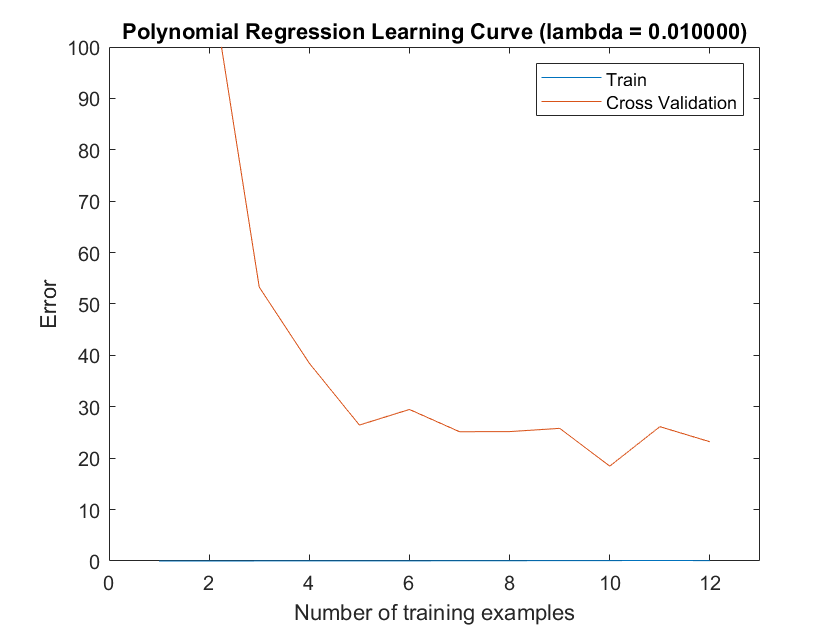

plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

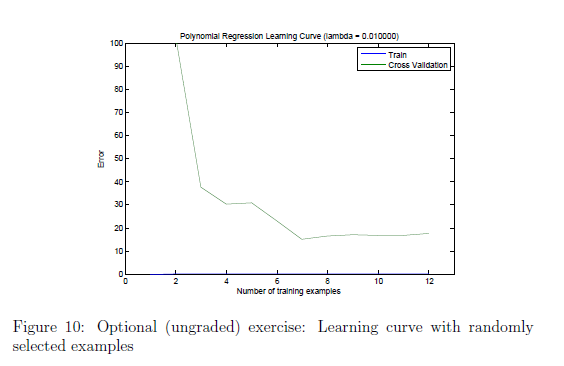

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

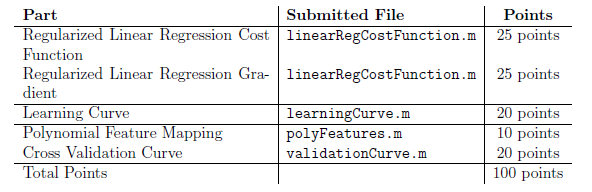

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.


.                          featureNormalize.m         linearRegCostFunction.m    validationCurve.m          
..                         fmincg.m                   plotFit.m                  
ex5.mlx                    learningCurve.m            polyFeatures.m             
ex5_companion.mlx          lib                        submit.m                   
ex5data1.mat               linearRegCostFunction.asv  trainLinearReg.m           

